# Machine Learning: Programming Exercise 4

## Neural Networks Learning

In this exercise, you will implement the backpropagation algorithm for neural networks and apply it to the task of hand-written digit recognition.

### Files needed for this exercise

- `ex4.mlx` - MATLAB Live Script that steps you through the exercise

- `ex4data1.mat` - Training set of hand-written digits

- `ex4weights.mat` - Neural network parameters for exercise 4

- `submit.m` - Submission script that sends your solutions to our servers

- `displayData.m` - Function to help visualize the dataset

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `sigmoid.m` - Sigmoid function

- `computeNumericalGradient.m` - Numerically compute gradients

- `checkNNGradients.m` - Function to help check your gradients

- `debugInitializeWeights.m` - Function for initializing weights

- `predict.m` - Neural network prediction function

- *`sigmoidGradient.m` - Compute the gradient of the sigmoid function

- *`randInitializeWeights.m` - Randomly initialize weights

- *`nnCostFunction.m` - Neural network cost function

**** indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex4' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

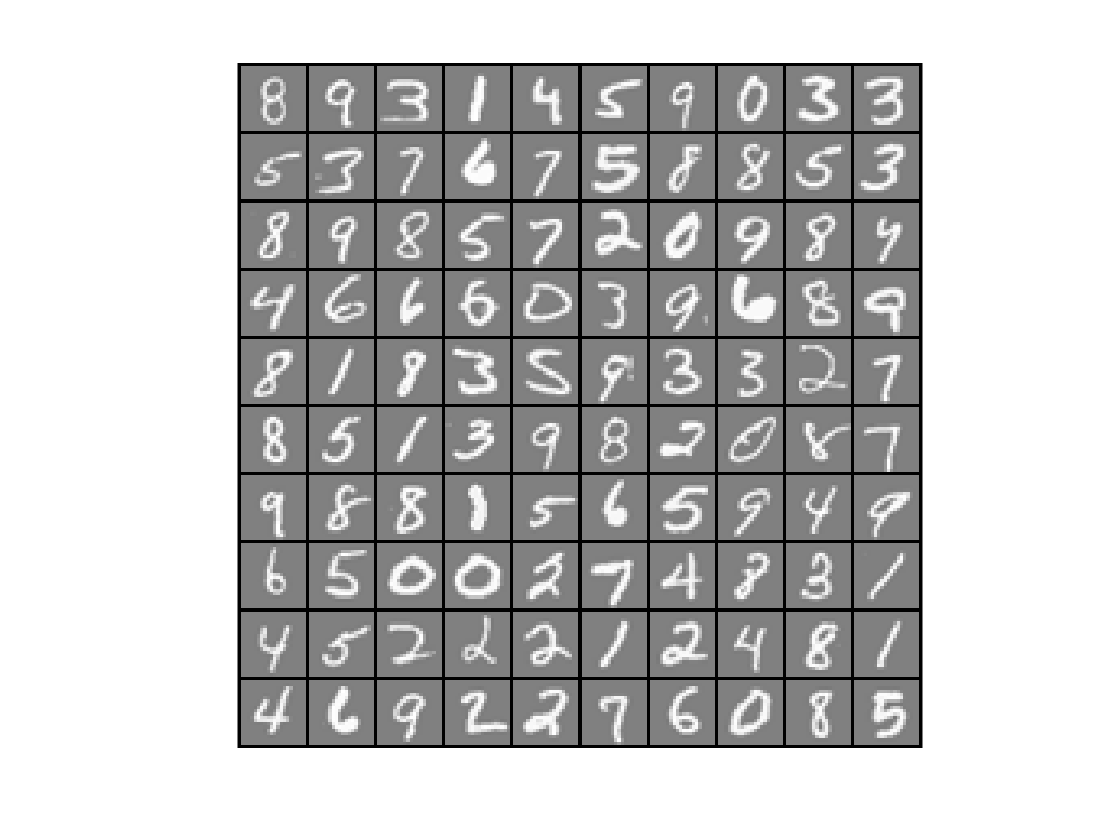

clear
dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Neural Networks

In the previous exercise, you implemented feedforward propagation for neural networks and used it to predict handwritten digits with the weights we provided. In this exercise, you will implement the backpropagation algorithm to learn the parameters for the neural network.

### 1.1 Visualizing the data

The code below will load the data and display it on a 2-dimensional plot (Figure 1) by calling the function `displayData`. This is the same dataset that you used in the previous exercise. Run the code below to load the training data into the variables `X` and `y.`

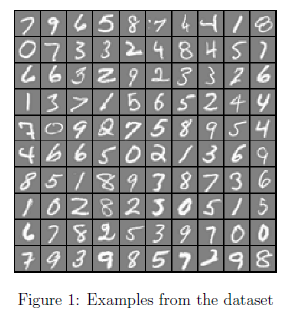

load('ex4data1.mat');
m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));

    There are 5000 training examples in `ex4data1.mat`, where each training example is a 20 pixel by 20 pixel grayscale image of the digit. Each pixel is represented by a floating point number indicating the grayscale intensity at that location. The 20 by 20 grid of pixels is 'unrolled' into a 400-dimensional vector. Each of these training examples becomes a single row in our data matrix `X`. This gives us a 5000 by 400 matrix `X` where every row is a training example for a handwritten digit image.


$$X=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T -\\
-{\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack$$


The second part of the training set is a 5000-dimensional vector `y` that contains labels for the training set. To make things more compatible with MATLAB indexing, where there is no zero index, we have mapped the digit zero to the value ten. Therefore, a '0' digit is labeled as '10', while the digits '1' to '9' are labeled as '1' to '9' in their natural order.

### 1.2 Model representation

Our neural network is shown in Figure 2. It has 3 layers- an input layer, a hidden layer and an output layer. Recall that our inputs are pixel values of digit images. Since the images are of size 20 x 20, this gives us 400 input layer units (not counting the extra bias unit which always outputs +1). 

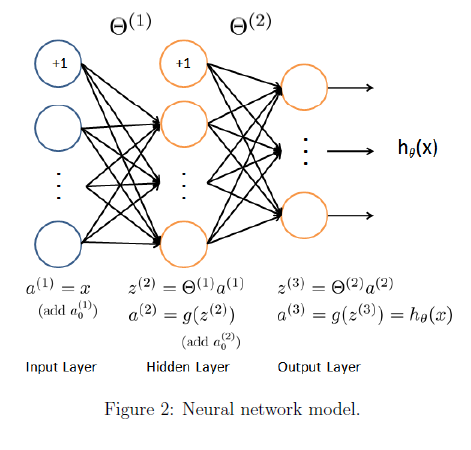

    You have been provided with a set of network parameters $(\Theta^{(1)},\Theta^{(2)})$ already trained by us. These are stored in `ex4weights.mat. ` Run the code below to load them into `Theta1` and `Theta2`. The parameters have dimensions that are sized for a neural network with 25 units in the second layer and 10 output units (corresponding to the 10 digit classes).

% Load the weights into variables Theta1 and Theta2
load('ex4weights.mat');

### 1.3 Feedforward and cost function

Now you will implement the cost function and gradient for the neural network. First, complete the code in `nnCostFunction.m` to return the cost. Recall that the cost function for the neural network (without regularization) is


$$J(\theta) =\frac{1}{m}{\sum_{i=1}^m\sum_{k=1}^K{\left[

-y_k^{(i)} \log((h_{\theta}(x^{(i)}))_k)- (1 -y_k^{(i)}) \log(1- (h_{\theta}(x^{(i)}))_k)\right]},$$


where $h_\theta(x^{(i)})$ is computed as shown in the Figure 2 and $K = 10$ is the total number of possible labels. Note that $h_\theta(x^{(i)})_k = a^{(3)}_k$ is the activation (output value) of the $k$-th output unit. Also, recall that whereas the original labels (in the variable `y`) were $1, 2, \ldots, 10,$ for the purpose of training a neural network, we need to recode the labels as vectors containing only values 0 or 1, so that


$$y=\left\lbrack \begin{array}{c}
1\\
0\\
0\\
\vdots \\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\\
1\\
0\\
\vdots \\
0
\end{array}\right\rbrack ,\dots \textrm{or}\;\left\lbrack \begin{array}{c}
0\\
0\\
0\\
\vdots \\
1
\end{array}\right\rbrack$$


    For example, if $x^{(i)}$ is an image of the digit 5, then the corresponding $y^{(i)}$ (that you should use with the cost function) should be a 10-dimensional vector with $y_5 = 1$, and the other elements equal to 0. You should implement the feedforward computation that computes $h_\theta(x^{(i)})$ for every example $i$ and sum the cost over all examples. Your code should also work for a dataset of any size, with any number of labels (you can assume that there are always at least $K\geq 3$ labels). 

**Implementation Note:** The matrix `X` contains the examples in rows (i.e., `X(i,:)'` is the `i`-th training example $x^{(i)}$, expressed as a $n$ x 1 vector.) When you complete the code in `nnCostFunction.m`, you will need to add the column of 1's to the `X` matrix. The parameters for each unit in the neural network is represented in `Theta1` and `Theta2` as one row. Specifically, the first row of `Theta1` corresponds to the first hidden unit in the second layer. You can use a `for` loop over the examples to compute the cost.  We suggest implementing the feedforward cost *without* regularization first so that it will be easier for you to debug. Later, you will get to implement the regularized cost.

    Once you are done, run the code below to call your `nnCostFunction` using the loaded set of parameters for `Theta1` and `Theta2`. You should see that the cost is about 0.287629.

input_layer_size  = 400;  % 20x20 Input Images of Digits

z2 =    -2.9368   -4.8130   -4.2406   -3.0345   -6.2729   -5.5205   -5.1122   -5.1449   -5.6325   -6.0249   -5.7097   -3.6987   -4.6623   -2.6256   -5.8646   -3.5273   -5.9762   -8.5508   -4.0622   -5.6531   -1.6293   -6.4097   -5.6625   -2.2469   -3.6892   -4.4806   -0.4680   -2.9304   -5.0725   -4.8333   -1.7819   -4.9119   -4.8121   -0.9689   -5.1899   -2.9802   -2.9812   -5.8911   -5.6872   -4.0943   -6.1219   -5.5565   -5.0302   -0.9387   -5.4181   -5.5378   -4.2178   -1.3720   -3.0310   -2.2602
   -2.4506   -2.9226   -3.6870   -5.6188   -2.4730   -7.4163   -4.5838   -4.4040   -3.0610   -0.1681   -0.9050   -4.9493   -2.8642   -7.4188   -3.9115   -3.0805   -3.5173   -6.8673   -1.4970   -1.0970   -4.9441   -2.3396   -3.7902   -2.1188   -1.1411   -5.7880   -2.9972   -2.9172   -3.1600   -4.6096   -3.6122   -9.8265   -5.4071   -6.2495   -3.8326   -3.7441   -3.4365   -2.4680   -5.7112   -8.4842   -6.4090   -5.1105   -9.3151   -4.3050   -1.7657   -5.6827   -6.8900  -10.0408   -2.0765   -

a2 =     1.0000    0.0504    0.0794    0.9930    0.5187    0.7052    0.9965    0.0107    0.0016    0.9965    0.0204    0.0718    0.0217    0.0462    0.0503    0.0042    0.8870    0.9920    0.0969    0.8479    0.7977    0.0238    0.9838    0.9725    0.9434    0.1072
    1.0000    0.0081    0.0510    0.9337    0.7003    0.2539    0.9963    0.1325    0.0007    0.9972    0.0118    0.1322    0.0166    0.0221    0.0932    0.0029    0.9360    0.9973    0.1322    0.3176    0.7877    0.0110    0.9341    0.8914    0.9910    0.0595
    1.0000    0.0142    0.0244    0.9975    0.8844    0.9152    0.9809    0.0111    0.0114    0.9575    0.0800    0.4984    0.2404    0.0204    0.0157    0.0039    0.7990    0.8720    0.0238    0.0127    0.0169    0.0929    0.9655    0.8243    0.9565    0.0887
    1.0000    0.0459    0.0036    0.9957    0.8989    0.8630    0.9817    0.0119    0.0133    0.6776    0.0129    0.1362    0.0156    0.0652    0.0248    0.0006    0.9656    0.9845    0.0238    0.0163    0.5532  

hidden_layer_size = 25;   % 25 hidden units
num_labels = 10;          % 10 labels, from 1 to 10 (note that we have mapped "0" to label 10)

Cost at parameters (loaded from ex4weights): 0.287629


% Unroll parameters 
nn_params = [Theta1(:) ; Theta2(:)];

% Weight regularization parameter (we set this to 0 here).
lambda = 0;

J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

fprintf('Cost at parameters (loaded from ex4weights): %f', J);

z2 =    -2.9368   -4.8130   -4.2406   -3.0345   -6.2729   -5.5205   -5.1122   -5.1449   -5.6325   -6.0249   -5.7097   -3.6987   -4.6623   -2.6256   -5.8646   -3.5273   -5.9762   -8.5508   -4.0622   -5.6531   -1.6293   -6.4097   -5.6625   -2.2469   -3.6892   -4.4806   -0.4680   -2.9304   -5.0725   -4.8333   -1.7819   -4.9119   -4.8121   -0.9689   -5.1899   -2.9802   -2.9812   -5.8911   -5.6872   -4.0943   -6.1219   -5.5565   -5.0302   -0.9387   -5.4181   -5.5378   -4.2178   -1.3720   -3.0310   -2.2602
   -2.4506   -2.9226   -3.6870   -5.6188   -2.4730   -7.4163   -4.5838   -4.4040   -3.0610   -0.1681   -0.9050   -4.9493   -2.8642   -7.4188   -3.9115   -3.0805   -3.5173   -6.8673   -1.4970   -1.0970   -4.9441   -2.3396   -3.7902   -2.1188   -1.1411   -5.7880   -2.9972   -2.9172   -3.1600   -4.6096   -3.6122   -9.8265   -5.4071   -6.2495   -3.8326   -3.7441   -3.4365   -2.4680   -5.7112   -8.4842   -6.4090   -5.1105   -9.3151   -4.3050   -1.7657   -5.6827   -6.8900  -10.0408   -2.0765   -

a2 =     1.0000    0.0504    0.0794    0.9930    0.5187    0.7052    0.9965    0.0107    0.0016    0.9965    0.0204    0.0718    0.0217    0.0462    0.0503    0.0042    0.8870    0.9920    0.0969    0.8479    0.7977    0.0238    0.9838    0.9725    0.9434    0.1072
    1.0000    0.0081    0.0510    0.9337    0.7003    0.2539    0.9963    0.1325    0.0007    0.9972    0.0118    0.1322    0.0166    0.0221    0.0932    0.0029    0.9360    0.9973    0.1322    0.3176    0.7877    0.0110    0.9341    0.8914    0.9910    0.0595
    1.0000    0.0142    0.0244    0.9975    0.8844    0.9152    0.9809    0.0111    0.0114    0.9575    0.0800    0.4984    0.2404    0.0204    0.0157    0.0039    0.7990    0.8720    0.0238    0.0127    0.0169    0.0929    0.9655    0.8243    0.9565    0.0887
    1.0000    0.0459    0.0036    0.9957    0.8989    0.8630    0.9817    0.0119    0.0133    0.6776    0.0129    0.1362    0.0156    0.0652    0.0248    0.0006    0.9656    0.9845    0.0238    0.0163    0.5532  

Cost at parameters (loaded from ex4weights): 0.383770

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 Regularized cost function

The cost function for neural networks with regularization is given by


$$J(\theta) =
\frac{1}{m}\sum_{i=1}^m
\sum_{k=1}^K 
\left[ -y^{(i)}_k \log((h_{\theta}(x^{(i)})_k)- (1 -y^{(i)}_k) \log(1-(h_{\theta}(x^{(i)}))_k)  \right]
\\ \qquad 
+\frac{\lambda}{2m} \left[\sum_{j=1}^{25} 
\sum_{k=1}^{400} {\left( \Theta_{j,k}^{(1)}\right)^2}+
\sum_{j=1}^{10} 
\sum_{k=1}^{25} {\left( \Theta_{j,k}^{(2)}\right)^2}\right]$$


You can assume that the neural network will only have 3 layers- an input layer, a hidden layer and an output layer. However, your code should work for any number of input units, hidden units and outputs units. While we have explicitly listed the indices above for $\Theta^{(1)}$ and $\Theta^{(2)}$ for clarity, do note that** your code should in general work with **$\Theta^{(1)}$ and $\Theta^{(2)}$ **of any size.**

    Note that you should not be regularizing the terms that correspond to the bias. For the matrices Theta1 and Theta2, this corresponds to the first column of each matrix. You should now add regularization to your cost function. Notice that you can first compute the unregularized cost function $J$ using your existing `nnCostFunction.m` and then later add the cost for the regularization terms. Once you are done, run the code below to call your `nnCostFunction` using the loaded set of parameters for `Theta1` and `Theta2`, and $\lambda= 1$. You should see that the cost is about 0.383770.

% Weight regularization parameter (we set this to 1 here).
lambda = 1;

J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
fprintf('Cost at parameters (loaded from ex4weights): %f', J);

temp =      1     2     3
     4     5     6


ans =     0.1966    0.1050    0.0452
    0.0177    0.0066    0.0025


*You should now submit your solutions.  Enter/confirm your login and token in the command window when prompted.*

## 2. Backpropagation

In this part of the exercise, you will implement the backpropagation algorithm to compute the gradient for the neural network cost function. You will need to complete the `nnCostFunction.m` so that it returns an appropriate value for `grad`. Once you have computed the gradient, you will be able to train the neural network by minimizing the cost function $J(\theta)$ using an advanced optimizer such as `fmincg`.

    You will first implement the backpropagation algorithm to compute the gradients for the parameters for the (unregularized) neural network. After you have verified that your gradient computation for the unregularized case is correct, you will implement the gradient for the regularized neural network.

### 2.1 Sigmoid gradient

To help you get started with this part of the exercise, you will first implement the sigmoid gradient function. The gradient for the sigmoid function can be computed as


$$g'(z)=\frac{d}{dz}g(z) = g(z)(1-g(z))$$


where


$$\mathrm{sigmoid}(z)=g(z)=\frac{1}{1+e^{-z}}$$


When you are done, try testing a few values by calling `sigmoidGradient(z)` below. For large values (both positive and negative) of `z`, the gradient should be close to 0. When `z = 0`, the gradient should be exactly 0.25. Your code should also work with vectors and matrices. For a matrix, your function should perform the sigmoid gradient function on every element.

% Call your sigmoidGradient function
temp = [1 2 3; 4 5 6]
sigmoidGradient(temp)

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.2 Random initialization

When training neural networks, it is important to randomly initialize the parameters for symmetry breaking. One effective strategy for random initialization is to randomly select values for $\Theta^{(l)}$ uniformly in the range $[-\epsilon_{int},\epsilon_{init}]$. You should use $\epsilon_{init} = 0.12$*. This range of values ensures that the parameters are kept small and makes the learning more efficient. 

Your job is to complete `randInitializeWeights.m` to initialize the weights for $\Theta$; modify the file and fill in the following code:

When you are done, run the code below to call `randInitialWeights` and initialize the neural network parameters.

initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);

% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];

z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0874    0.0765    0.0725    0.0792    0.0903
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5218    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5181    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0876    0.0767    0.0727    0.0794    0.0905
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5192    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1075    0.0984    0.0824    0.0741    0.0812
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5268    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1077    0.0986    0.0826    0.0743    0.0814
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5186    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0287    0.0298    0.0164    0.0008   -0.0026
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5074    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4993    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0289    0.0300    0.0166    0.0010   -0.0024
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5042    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5003    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0766   -0.0663   -0.0648   -0.0733   -0.0841
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0764   -0.0661   -0.0646   -0.0731   -0.0839
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4835    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4839    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1115   -0.1016   -0.0865   -0.0802   -0.0884


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4721
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4746
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1113   -0.1014   -0.0863   -0.0800   -0.0882


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4780


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0727    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0026
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0841
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4835    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0800   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0727    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0026
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0841
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4835    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0800   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0727    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0026
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0841
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4835    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0800   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0000   -0.0000
    0.0000    0.0000
   -0.0000   -0.0000
    0.0000    0.0000
   -0.0000   -0.0000
   -0.0002   -0.0002
    0.0002    0.0002
   -0.0003   -0.0003
    0.0003    0.0003
   -0.0004   -0.0004
   -0.0001   -0.0001
    0.0001    0.0001
   -0.0001   -0.0001
    0.0002    0.0002
   -0.0002   -0.0002
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1641    0.1641
    0.0576    0.0576
    0.0505    0.0505
    0.1646    0.1646
    0.0578    0.0578
    0.0508    0.0508
    0.1583    0.1583
    0.0559    0.0559
    0.0492    0.0492
    0.1511    0.1511
    0.0537    0.0537
    0.0471    0.0471
    0.1496    0.1496
    0.0532    0.0532
    0.0466    0.0466

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be

*One effective strategy for choosing $\epsilon_{init}$ is to base it on the number of units in the network. A good choice of $\epsilon_{init}$ is $\epsilon_{init} = \frac{\sqrt{6}}{\sqrt{L_{in}+L_{out}}},$ where $L_{in} = s_l$ and $L_{out} = s_l+1$ are the number of units in the layers adjacent to $\Theta^{(l)}$.

*You do not need to submit any code for this part of the exercise.*

### 2.3 Backpropagation

Now, you will implement the backpropagation algorithm. Recall that the intuition behind the backpropagation algorithm is as follows. Given a training example $(x^{(t)}, y^{(t)})$, we will first run a 'forward pass' to compute all the activations throughout the network, including the output value of the hypothesis $h_\Theta(x)$. Then, for each node $j$ in layer $l$, we would like to compute an 'error term' $\delta^{(l)}_j$ that measures how much that node was 'responsible' for any errors in our output.

    For an output node, we can directly measure the difference between the network's activation and the true target value, and use that to define $\delta^{(3)}_j$ (since layer 3 is the output layer). For the hidden units, you will compute $\delta^{(l)}_j$ based on a weighted average of the error terms of the nodes in layer $(l + 1)$.

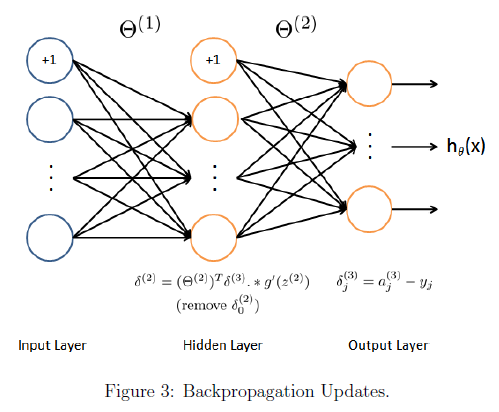

    In detail, here is the backpropagation algorithm (also depicted in Figure 3). You should implement steps 1 to 4 in a loop that processes one example at a time. Concretely, you should implement a `for` loop for `t = 1:m` and place steps 1-4 below inside the `for` loop, with the $t^{th}$ iteration performing the calculation on the $t^{th}$ training example $(x^{(t)}, y^{(t)})$. Step 5 will divide the accumulated gradients by $m$ to obtain the gradients for the neural network cost function.

- Set the input layer's values $(a^{(1)})$ to the $t$-th training example $x^{(t)}$. Perform a feedforward pass (Figure 2), computing the activations $(z^{(2)}, a^{(2)}, z^{(3)}, a^{(3)})$ for layers 2 and 3. Note that you need to add a $+1$ term to ensure that the vectors of activations for layers $a^{(1)}$ and $a^{(2)}$ also include the bias unit. In MATLAB, if `a_1` is a column vector, adding one corresponds to `a_1 = [1; a_1].`

- For each output unit $k$ in layer 3 (the output layer), set $\delta^{(3)}_k = (a_k^{(3)}-y_k)$ where $y_k\in \{0, 1\}$ indicates whether the current training example belongs to class $k$ $(y_k = 1)$, or if it belongs to a different class $(y_k = 0)$.You may find logical arrays helpful for this task (explained in the previous programming exercise).

- For the hidden layer $l = 2$, set $\delta^{(2)} = (\Theta^{(2)})^T \delta^{(3)}.*g'(z^{(2)})$

- Accumulate the gradient from this example using the following formula: $\Delta^{(l)} = \Delta^{(l)} + \delta^{(l+1)} (a^{(l)})^T$. Note that you should skip or remove $\delta_0^{(2)}$. In MATLAB, removing $\delta_0^{(2)}$ corresponds to `delta_2 = delta_2(2:end).`

- Obtain the (unregularized) gradient for the neural network cost function by dividing the accumulated gradients by $\frac{1}{m}:$ $\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij}$

**MATLAB Tip:** You should implement the backpropagation algorithm only after you have successfully completed the feedforward and cost functions. While implementing the backpropagation algorithm, it is often useful to use the size function to print out the sizes of the variables you are working with if you run into dimension mismatch errors (''nonconformant arguments") errors.

    After you have implemented the backpropagation algorithm, the code in the next section will run gradient checking on your implementation. The gradient check will allow you to increase your confidence that your code is computing the gradients correctly.

### 2.4 Gradient checking

In your neural network, you are minimizing the cost function $J(\Theta)$. To perform gradient checking on your parameters, you can imagine 'unrolling' the parameters $\Theta^{(1)},\Theta^{(2)}$ into a long vector $\theta$. By doing so, you can think of the cost function being $J(\theta)$ instead and use the following gradient checking procedure.

    Suppose you have a function $f_i(\theta)$ that purportedly computes $\frac{\partial}{\partial\theta_i}J(\theta)$; you'd like to check if $f_i$ is outputting correct derivative values.


$$\textrm{Let}\;\theta^{i+} =\theta +\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
\epsilon \\
\vdots \\
0
\end{array}\right\rbrack \;\textrm{and}\;\theta^{i-} =\theta -\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
\epsilon \\
\vdots \\
0
\end{array}\right\rbrack$$


    So, $\theta^{(i+)}$ is the same as $\theta$, except its $i$-th element has been incremented by $\epsilon$. Similarly, $\theta^{(i-)}$is the corresponding vector with the $i$-th element decreased by $\epsilon$. You can now numerically verify $f_i(\theta)$'s correctness by checking, for each $i$, that:


$$f_i(\theta) \approx \frac{J(\theta^{(i+)})-J(\theta^{(i-)})}{2\epsilon}$$


The degree to which these two values should approximate each other will depend on the details of $J$. But assuming $\epsilon= 10^{-4}$, you'll usually find that the left- and right-hand sides of the above will agree to at least 4 signicant digits (and often many more). We have implemented the function to compute the numerical gradient for you in `computeNumericalGradient.m`. While you are not required to modify the file, we highly encourage you to take a look at the code to understand how it works.

   The code below will run the provided function `checkNNGradients.m` which will create a small neural network and dataset that will be used for checking your gradients. If your backpropagation implementation is correct, you should see a relative dierence that is less than 1e-9.

checkNNGradients;

z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0874    0.0765    0.0725    0.0792    0.0903
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5218    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5181    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0876    0.0767    0.0727    0.0794    0.0905
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5192    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1075    0.0984    0.0824    0.0741    0.0812
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5268    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1077    0.0986    0.0826    0.0743    0.0814
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5186    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0287    0.0298    0.0164    0.0008   -0.0026
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5074    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4993    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0289    0.0300    0.0166    0.0010   -0.0024
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5042    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5003    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0766   -0.0663   -0.0648   -0.0733   -0.0841
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0764   -0.0661   -0.0646   -0.0731   -0.0839
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4835    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4839    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1115   -0.1016   -0.0865   -0.0802   -0.0884


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4721
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4746
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1113   -0.1014   -0.0863   -0.0800   -0.0882


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4780


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0727    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0026
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0841
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4835    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0800   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0727    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0026
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0841
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4835    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0800   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0727    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0026
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0841
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4835    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0800   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


z2 =     0.0875    0.0766    0.0726    0.0793    0.0904
    0.1076    0.0985    0.0825    0.0742    0.0813
    0.0288    0.0299    0.0165    0.0009   -0.0025
   -0.0765   -0.0662   -0.0647   -0.0732   -0.0840
   -0.1114   -0.1015   -0.0864   -0.0801   -0.0883


a2 =     1.0000    0.5219    0.5269    0.5072    0.4809    0.4722
    1.0000    0.5191    0.5246    0.5075    0.4834    0.4747
    1.0000    0.5182    0.5206    0.5041    0.4838    0.4784
    1.0000    0.5198    0.5185    0.5002    0.4817    0.4800
    1.0000    0.5226    0.5203    0.4994    0.4790    0.4779


   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0168   -0.0168
    0.0394    0.0394
    0.0593    0.0593
    0.0248    0.0248
   -0.0327   -0.0327
   -0.0602   -0.0602
   -0.0320   -0.0320
    0.0249    0.0249
    0.0598    0.0598
    0.0386    0.0386
   -0.0174   -0.0174
   -0.0576   -0.0576
   -0.0452   -0.0452
    0.0091    0.0091
    0.0546    0.0546
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1187    0.1187
    0.0000    0.0000
    0.0337    0.0337
    0.2040    0.2040
    0.1171    0.1171
    0.0755    0.0755
    0.1257    0.1257
   -0.0041   -0.0041
    0.0170    0.0170
    0.1763    0.1763
    0.1131    0.1131
    0.0862    0.0862
    0.1323    0.1323
   -0.0045   -0.0045
    0.0015    0.0015

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be

z2 =    -2.9368   -4.8130   -4.2406   -3.0345   -6.2729   -5.5205   -5.1122   -5.1449   -5.6325   -6.0249   -5.7097   -3.6987   -4.6623   -2.6256   -5.8646   -3.5273   -5.9762   -8.5508   -4.0622   -5.6531   -1.6293   -6.4097   -5.6625   -2.2469   -3.6892   -4.4806   -0.4680   -2.9304   -5.0725   -4.8333
   -2.4506   -2.9226   -3.6870   -5.6188   -2.4730   -7.4163   -4.5838   -4.4040   -3.0610   -0.1681   -0.9050   -4.9493   -2.8642   -7.4188   -3.9115   -3.0805   -3.5173   -6.8673   -1.4970   -1.0970   -4.9441   -2.3396   -3.7902   -2.1188   -1.1411   -5.7880   -2.9972   -2.9172   -3.1600   -4.6096
    4.9551    2.6445    5.9966    5.4439    4.4582    9.3259    1.8262    5.8413    5.4993    1.3531    5.3112    5.2754    5.9002    7.1311    7.2226    5.4906    5.8636   13.7559    5.5835    4.7860    5.7486    6.2138    7.2068    3.8810    5.7479    6.0420    3.9763    2.9083    6.7407    7.4338
    0.0749    0.8486    2.0348    2.1852    0.8078   -0.1708    1.9035    1.7398    0.3585  

a2 =     1.0000    0.0504    0.0794    0.9930    0.5187    0.7052    0.9965    0.0107    0.0016    0.9965    0.0204    0.0718    0.0217    0.0462    0.0503    0.0042    0.8870    0.9920    0.0969    0.8479    0.7977    0.0238    0.9838    0.9725    0.9434    0.1072
    1.0000    0.0081    0.0510    0.9337    0.7003    0.2539    0.9963    0.1325    0.0007    0.9972    0.0118    0.1322    0.0166    0.0221    0.0932    0.0029    0.9360    0.9973    0.1322    0.3176    0.7877    0.0110    0.9341    0.8914    0.9910    0.0595
    1.0000    0.0142    0.0244    0.9975    0.8844    0.9152    0.9809    0.0111    0.0114    0.9575    0.0800    0.4984    0.2404    0.0204    0.0157    0.0039    0.7990    0.8720    0.0238    0.0127    0.0169    0.0929    0.9655    0.8243    0.9565    0.0887
    1.0000    0.0459    0.0036    0.9957    0.8989    0.8630    0.9817    0.0119    0.0133    0.6776    0.0129    0.1362    0.0156    0.0652    0.0248    0.0006    0.9656    0.9845    0.0238    0.0163    0.5532  

Cost at (fixed) debugging parameters (w/ lambda = 3): 0.576051

**Practical Tip:** When performing gradient checking, it is much more efficient to use a small neural network with a relatively small number of input units and hidden units, thus having a relatively small number of parameters. Each dimension of $\theta$ requires two evaluations of the cost function and this can be expensive. In the function `checkNNGradients`, our code creates a small random model and dataset which is used with `computeNumericalGradient` for gradient checking. Furthermore, after you are condent that your gradient computations are correct, you should turn off gradient checking before running your learning algorithm.

**Practical Tip: **Gradient checking works for any function where you are computing the cost and the gradient. Concretely, you can use the same `computeNumericalGradient.m` function to check if your gradient implementations for the other exercises are correct too (e.g. logistic regression's cost function). Once your cost function passes the gradient check for the (unregularized) neural network cost function, you should submit the neural network gradient function (backpropagation).

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.5 Regularized neural networks

After you have successfully implemeted the backpropagation algorithm, you will add regularization to the gradient. To account for regularization, it turns out that you can add this as an additional term after computing the gradients using backpropagation. Specically, after you have computed $\Delta^{(l)}_{ij}
$ using backpropagation, you should add regularization using


$$\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij} \text{  for  } j = 0,\\
\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij} +\frac{\lambda}{m}\Theta^{(l)}_{ij} \text{  for  } j \geq 1$$


Note that you should *not* be regularizing the first column of $\Theta^{(l)}$ which is used for the bias term. Furthermore, in the parameters $\Theta^{(l)}_{ij}$, $i$ is indexed starting from 1, and $j$ is indexed starting from 0. Thus,


$$\Theta^{\left(l\right)} =\left\lbrack \begin{array}{ccc}
\Theta_{1,0}^{\left(l\right)}  & \Theta_{1,1}^{\left(l\right)}  & \cdots \\
\Theta_{2,0}^{\left(l\right)}  & \Theta_{2,1}^{\left(l\right)}  & \;\\
\vdots  & \; & \ddots 
\end{array}\right\rbrack$$


Somewhat confusingly, indexing in MATLAB starts from 1 (for both $i$ and $j$), thus `Theta1(2, 1)` actually corresponds to $\Theta^{(l)}_{2,0}$ (i.e., the entry in the second row, first column of the matrix $\Theta^{(1)}$ shown above)

    Now, modify your code that computes `grad` in `nnCostFunction` to account for regularization. After you are done, run the code below to run gradient checking on your implementation. If your code is correct, you should expect to see a relative difference that is less than 1e-9.

%  Check gradients by running checkNNGradients
lambda = 3;
checkNNGradients(lambda);
% Also output the costFunction debugging value 
% This value should be about 0.576051
debug_J  = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
fprintf('Cost at (fixed) debugging parameters (w/ lambda = 3): %f', debug_J);

z2 =     0.4241    0.3134    0.7758    1.0492   -0.0600   -0.0531    0.2409    0.6022    0.8709    0.5424    0.5789    0.1378    0.9698    0.4798    0.4742    0.2161    0.7226    0.6409   -0.0533    1.2262    0.6489   -0.1140    0.4500    0.0237    0.2724    0.3863    0.7389    0.3812    0.1258    0.4611    0.1438    0.4277    0.5809    0.5335    0.9900    0.8658    0.6187    0.4091    0.9286    0.8900    0.4428    0.1801    0.3867    1.1604    0.3914    0.0976    0.6471    0.9565    0.5198    0.1741
    0.1932   -0.5614   -0.0582    0.2839    0.1807    0.6172    0.1551    0.1862    0.3836    0.3545    0.4005    0.3096    0.4429    0.3716    0.1925   -0.1959   -0.2028    0.1275   -0.2629    0.4406    0.1958    0.3994    0.3634    0.2364    0.4636    0.6171    0.2112   -0.0409    0.5050    0.3631    0.1173    0.0884    0.2221   -0.1442    0.2488   -0.0552    0.2470    0.5331    0.1462   -0.0550    0.2529    0.1911    0.3815   -0.2001   -0.1370    0.4056    0.0700    0.2357   -0.2333   -

a2 =     1.0000    0.6045    0.5481    0.4773    0.5073    0.6098    0.5313    0.4152    0.5296    0.3888    0.4965    0.6727    0.2955    0.5378    0.5744    0.4624    0.5431    0.3542    0.6607    0.6632    0.4088    0.4092    0.4201    0.4082    0.3532    0.6628
    1.0000    0.5777    0.3632    0.4984    0.4544    0.6688    0.6294    0.3222    0.5922    0.4279    0.4559    0.7508    0.3177    0.5377    0.5274    0.4813    0.5458    0.3444    0.7072    0.7003    0.3563    0.4282    0.3534    0.4728    0.4103    0.6681
    1.0000    0.6848    0.4854    0.3114    0.4783    0.5335    0.4621    0.3533    0.6402    0.4021    0.3813    0.6857    0.4425    0.5045    0.5508    0.4729    0.5329    0.3694    0.6151    0.6492    0.5929    0.4862    0.2854    0.2715    0.4103    0.4665
    1.0000    0.7406    0.5705    0.4232    0.4136    0.6043    0.4294    0.3555    0.5825    0.4248    0.4454    0.6732    0.3205    0.5246    0.5466    0.4497    0.5567    0.4406    0.6111    0.6052    0.4033  

z2 =     0.3944    0.2806    0.7407    1.0134   -0.0968   -0.0863    0.2020    0.5862    0.8324    0.5100    0.5442    0.1104    0.9335    0.4606    0.4416    0.1931    0.6849    0.6079   -0.0757    1.1901    0.6194   -0.1409    0.4206    0.0079    0.2490    0.3584    0.7224    0.3558    0.1116    0.4360    0.1316    0.3943    0.5424    0.5053    0.9516    0.8336    0.5918    0.3788    0.8886    0.8465    0.4085    0.1500    0.3549    1.1259    0.3646    0.0651    0.6125    0.9273    0.4924    0.1538
    0.1798   -0.5764   -0.0719    0.2695    0.1637    0.6025    0.1380    0.1794    0.3679    0.3401    0.3858    0.2977    0.4280    0.3638    0.1774   -0.2058   -0.2199    0.1136   -0.2734    0.4259    0.1838    0.3870    0.3506    0.2297    0.4544    0.6046    0.2055   -0.0513    0.4989    0.3520    0.1120    0.0746    0.2062   -0.1558    0.2325   -0.0680    0.2352    0.5192    0.1296   -0.0729    0.2381    0.1779    0.3687   -0.2137   -0.1490    0.3916    0.0548    0.2240   -0.2454   -

a2 =     1.0000    0.5973    0.5448    0.4722    0.4967    0.6168    0.5504    0.4163    0.5194    0.3876    0.4767    0.6621    0.2988    0.5631    0.5806    0.4565    0.5460    0.3577    0.6462    0.6575    0.4025    0.4227    0.4127    0.4037    0.3457    0.6676
    1.0000    0.5697    0.3598    0.4931    0.4430    0.6758    0.6486    0.3232    0.5815    0.4265    0.4346    0.7409    0.3215    0.5651    0.5342    0.4749    0.5489    0.3481    0.6929    0.6944    0.3498    0.4431    0.3460    0.4678    0.4016    0.6732
    1.0000    0.6771    0.4820    0.3064    0.4646    0.5426    0.4863    0.3544    0.6279    0.4000    0.3569    0.6725    0.4468    0.5376    0.5580    0.4653    0.5368    0.3740    0.5961    0.6414    0.5850    0.5042    0.2772    0.2672    0.3998    0.4741
    1.0000    0.7337    0.5670    0.4173    0.4006    0.6131    0.4530    0.3566    0.5698    0.4228    0.4205    0.6601    0.3245    0.5569    0.5539    0.4422    0.5607    0.4454    0.5921    0.5973    0.3955  

z2 =     0.3348    0.2152    0.6705    0.9419   -0.1706   -0.1528    0.1243    0.5542    0.7554    0.4453    0.4748    0.0555    0.8609    0.4222    0.3763    0.1471    0.6095    0.5419   -0.1205    1.1178    0.5603   -0.1947    0.3617   -0.0236    0.2023    0.3025    0.6892    0.3051    0.0831    0.3856    0.1072    0.3274    0.4654    0.4491    0.8749    0.7694    0.5380    0.3181    0.8086    0.7596    0.3400    0.0898    0.2912    1.0571    0.3110   -0.0001    0.5432    0.8690    0.4377    0.1132
    0.1531   -0.6065   -0.0993    0.2406    0.1299    0.5731    0.1039    0.1659    0.3366    0.3114    0.3563    0.2741    0.3982    0.3483    0.1471   -0.2256   -0.2542    0.0857   -0.2942    0.3964    0.1600    0.3623    0.3250    0.2164    0.4360    0.5794    0.1940   -0.0723    0.4865    0.3300    0.1014    0.0468    0.1745   -0.1790    0.1999   -0.0935    0.2116    0.4916    0.0962   -0.1089    0.2085    0.1516    0.3430   -0.2408   -0.1731    0.3635    0.0244    0.2006   -0.2695   -

a2 =     1.0000    0.5829    0.5382    0.4621    0.4756    0.6308    0.5881    0.4186    0.4991    0.3850    0.4372    0.6405    0.3054    0.6125    0.5929    0.4447    0.5518    0.3647    0.6163    0.6459    0.3900    0.4499    0.3981    0.3948    0.3308    0.6771
    1.0000    0.5536    0.3529    0.4824    0.4205    0.6897    0.6857    0.3252    0.5598    0.4236    0.3926    0.7206    0.3290    0.6188    0.5476    0.4620    0.5550    0.3554    0.6630    0.6825    0.3370    0.4732    0.3313    0.4578    0.3842    0.6834
    1.0000    0.6616    0.4752    0.2966    0.4374    0.5608    0.5348    0.3564    0.6027    0.3958    0.3105    0.6454    0.4554    0.6026    0.5722    0.4500    0.5448    0.3832    0.5571    0.6255    0.5691    0.5402    0.2613    0.2588    0.3790    0.4892
    1.0000    0.7195    0.5599    0.4057    0.3750    0.6303    0.5009    0.3588    0.5441    0.4189    0.3721    0.6332    0.3326    0.6199    0.5686    0.4275    0.5685    0.4551    0.5532    0.5814    0.3801  

z2 =     0.1661    0.0298    0.4715    0.7392   -0.3796   -0.3414   -0.0961    0.4634    0.5373    0.2619    0.2782   -0.1001    0.6551    0.3134    0.1911    0.0166    0.3957    0.3549   -0.2474    0.9128    0.3931   -0.3473    0.1949   -0.1128    0.0699    0.1442    0.5953    0.1614    0.0023    0.2431    0.0380    0.1379    0.2471    0.2895    0.6575    0.5873    0.3857    0.1462    0.5820    0.5131    0.1457   -0.0809    0.1108    0.8619    0.1591   -0.1847    0.3467    0.7036    0.2827   -0.0020
    0.0774   -0.6918   -0.1768    0.1588    0.0339    0.4897    0.0071    0.1276    0.2480    0.2301    0.2728    0.2070    0.3137    0.3042    0.0613   -0.2818   -0.3511    0.0067   -0.3531    0.3129    0.0925    0.2922    0.2526    0.1787    0.3838    0.5082    0.1614   -0.1316    0.4515    0.2675    0.0712   -0.0318    0.0846   -0.2448    0.1074   -0.1660    0.1448    0.4132    0.0016   -0.2106    0.1247    0.0771    0.2703   -0.3177   -0.2414    0.2840   -0.0618    0.1344   -0.3379   -

a2 =     1.0000    0.5414    0.5193    0.4336    0.4164    0.6692    0.6883    0.4250    0.4416    0.3778    0.3311    0.5762    0.3246    0.7382    0.6270    0.4116    0.5682    0.3848    0.5277    0.6120    0.3552    0.5283    0.3576    0.3698    0.2907    0.7030
    1.0000    0.5074    0.3336    0.4523    0.3588    0.7270    0.7779    0.3309    0.4973    0.4155    0.2836    0.6579    0.3508    0.7530    0.5854    0.4258    0.5724    0.3767    0.5717    0.6473    0.3021    0.5589    0.2915    0.4298    0.3366    0.7113
    1.0000    0.6157    0.4559    0.2698    0.3628    0.6114    0.6659    0.3622    0.5287    0.3840    0.1994    0.5639    0.4798    0.7630    0.6117    0.4074    0.5671    0.4097    0.4444    0.5791    0.5233    0.6389    0.2195    0.2361    0.3228    0.5323
    1.0000    0.6768    0.5396    0.3735    0.3066    0.6774    0.6336    0.3652    0.4704    0.4078    0.2502    0.5527    0.3559    0.7732    0.6095    0.3865    0.5904    0.4825    0.4411    0.5356    0.3378  

Iteration     1 | Cost: 3.312223e+00


z2 =    17.6019   18.6347   25.7283   24.0948   22.3142   20.3744   24.5165    9.1462   28.0245   20.9160   24.2445   16.0172   25.4950   11.1185   19.4208   14.1355   22.1137   18.9477   12.6275   26.2406   18.8973   15.3538   16.5852   10.3102   17.4913   16.5677   13.3489   16.7229    8.5232   14.6514    6.9314   18.8520   23.5904   17.0148   23.7004   22.5578   17.4050   17.9352   24.7238   27.2955   19.2828   16.9154   19.3643   24.9035   15.2118   18.8707   20.0932   17.0377   16.0234   12.2322
   15.8532   15.9334   22.9319   21.8689   19.9169   18.9614   21.9212    8.4751   24.9875   18.5325   21.6360   15.1068   22.9368   10.7816   16.9886   12.6476   19.2334   17.6663   11.0690   23.2422   17.6378   14.2193   15.6146    9.6011   16.0870   15.2486   12.2248   15.1559    8.2353   13.5411    6.4382   18.0339   22.1849   15.6566   21.5893   20.1689   15.4328   16.3125   22.6762   24.9280   18.1673   15.9284   18.5403   21.8341   13.5572   18.0019   18.1822   16.1380   14.1704   1

a2 =     1.0000    1.0000    1.0000    0.9997    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9992    1.0000    1.0000
    1.0000    1.0000    1.0000    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9997    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000  

z2 =     4.3810    4.5273    6.5771    6.3852    5.1065    4.6665    5.8538    2.5624    7.1821    5.2548    6.0718    3.7962    6.6599    2.9254    4.8397    3.4297    5.6459    4.8495    2.8650    7.0356    4.8663    3.4483    4.1571    2.4068    4.2814    4.1144    3.6784    4.1650    2.0622    3.7261    1.7044    4.6619    5.8901    4.3327    6.2279    5.8985    4.5000    4.4466    6.4180    6.9875    4.7720    4.0278    4.7652    6.6738    3.7980    4.4217    5.1203    4.6522    4.0879    2.9555
    3.8910    3.3272    5.4096    5.4070    4.8404    4.9551    5.3046    2.1456    6.2285    4.6546    5.4372    3.8089    5.7827    2.8370    4.1533    2.8437    4.3833    4.2758    2.4081    5.8559    4.3339    3.6589    3.9662    2.4564    4.1799    4.0716    3.0776    3.5640    2.3332    3.4762    1.6104    4.3354    5.4271    3.5992    5.3005    4.7498    3.8405    4.2567    5.4830    5.8664    4.4863    3.9091    4.6869    5.0373    3.0943    4.5671    4.3486    4.0031    3.1694    

a2 =     1.0000    0.9876    0.9800    0.8532    0.9596    0.9967    0.9910    0.9676    0.9798    0.9538    0.9035    0.9874    0.9468    0.9850    0.9963    0.9476    0.9828    0.8974    0.9395    0.9926    0.9287    0.9738    0.8878    0.7880    0.9300    0.9888
    1.0000    0.9893    0.9653    0.8967    0.9619    0.9982    0.9959    0.9612    0.9884    0.9704    0.9050    0.9936    0.9652    0.9896    0.9969    0.9621    0.9867    0.9085    0.9665    0.9956    0.9317    0.9836    0.8848    0.8547    0.9539    0.9919
    1.0000    0.9986    0.9955    0.8987    0.9814    0.9985    0.9949    0.9798    0.9952    0.9768    0.9049    0.9971    0.9813    0.9944    0.9980    0.9796    0.9947    0.9519    0.9781    0.9971    0.9885    0.9936    0.8834    0.8409    0.9759    0.9945
    1.0000    0.9983    0.9955    0.9134    0.9719    0.9989    0.9945    0.9799    0.9929    0.9787    0.9288    0.9963    0.9735    0.9945    0.9983    0.9753    0.9949    0.9634    0.9677    0.9964    0.9691  

z2 =     1.2051    1.1385    1.9766    2.1310    0.9728    0.8931    1.3706    0.9808    2.1753    1.4927    1.7064    0.8604    2.1354    0.9573    1.3371    0.8580    1.6900    1.4629    0.5198    2.4222    1.4958    0.5883    1.1716    0.5083    1.1081    1.1229    1.3554    1.1484    0.5101    1.1017    0.4488    1.2531    1.6382    1.2862    2.0307    1.8966    1.3999    1.2063    2.0207    2.1091    1.2862    0.9320    1.2582    2.2946    1.0561    0.9508    1.5235    1.6770    1.2207    0.7271
    1.0175    0.2989    1.2003    1.4526    1.2187    1.5905    1.3130    0.6251    1.7223    1.3208    1.5459    1.0949    1.6619    0.9286    1.0700    0.4887    0.8160    1.0591    0.3276    1.6793    1.1381    1.1221    1.1681    0.7402    1.3196    1.3867    0.8803    0.7794    0.9154    1.0585    0.4507    1.0447    1.4016    0.7028    1.3876    1.0458    1.0558    1.3606    1.3529    1.2875    1.1999    1.0218    1.3591    1.0024    0.5809    1.3399    1.0254    1.0881    0.5267    

a2 =     1.0000    0.7694    0.7345    0.5579    0.6286    0.8740    0.8527    0.6478    0.6857    0.5916    0.5054    0.7869    0.5393    0.8598    0.8546    0.6093    0.7692    0.5451    0.6813    0.8251    0.5457    0.7265    0.5172    0.4805    0.4913    0.8524
    1.0000    0.7574    0.5742    0.5959    0.5887    0.9083    0.9085    0.5649    0.7482    0.6464    0.4644    0.8501    0.5879    0.8768    0.8431    0.6393    0.7826    0.5465    0.7401    0.8577    0.5033    0.7664    0.4584    0.5557    0.5587    0.8659
    1.0000    0.8783    0.7686    0.4471    0.6350    0.8753    0.8605    0.6297    0.8024    0.6377    0.3794    0.8362    0.7142    0.8965    0.8665    0.6618    0.8169    0.6132    0.6832    0.8428    0.7629    0.8420    0.3878    0.3835    0.5877    0.7989
    1.0000    0.8939    0.8104    0.5476    0.5642    0.9033    0.8446    0.6323    0.7559    0.6598    0.4517    0.8237    0.6086    0.9007    0.8700    0.6360    0.8285    0.6800    0.6592    0.8170    0.5848  

z2 =     0.6760    0.5739    1.2102    1.4223    0.2841    0.2645    0.6237    0.7173    1.3412    0.8659    0.9791    0.3713    1.3816    0.6294    0.7535    0.4295    1.0309    0.8987    0.1291    1.6536    0.9343    0.1119    0.6742    0.1920    0.5794    0.6245    0.9683    0.6458    0.2515    0.6644    0.2396    0.6852    0.9298    0.7787    1.3314    1.2299    0.8834    0.6665    1.2880    1.2964    0.7054    0.4162    0.6739    1.5651    0.5993    0.3726    0.9243    1.1813    0.7431    0.3558
    0.5388   -0.2056    0.4991    0.7937    0.6154    1.0299    0.6480    0.3718    0.9715    0.7654    0.8976    0.6427    0.9754    0.6106    0.5563    0.0963    0.2217    0.5232   -0.0191    0.9835    0.6057    0.6995    0.7019    0.4542    0.8430    0.9393    0.5142    0.3155    0.6792    0.6557    0.2574    0.4965    0.7310    0.2202    0.7357    0.4287    0.5919    0.8782    0.6648    0.5246    0.6524    0.5407    0.8047    0.3302    0.1621    0.8022    0.4718    0.6024    0.0864   -

a2 =     1.0000    0.6629    0.6315    0.4945    0.5216    0.7874    0.7799    0.5362    0.5654    0.4819    0.4140    0.6895    0.4266    0.8050    0.7565    0.5090    0.6750    0.4625    0.6057    0.7298    0.4468    0.6311    0.4343    0.4232    0.3843    0.7857
    1.0000    0.6397    0.4488    0.5233    0.4701    0.8354    0.8538    0.4426    0.6292    0.5305    0.3677    0.7658    0.4653    0.8221    0.7312    0.5321    0.6851    0.4588    0.6594    0.7669    0.3966    0.6690    0.3696    0.4914    0.4428    0.7981
    1.0000    0.7703    0.6222    0.3518    0.4962    0.7662    0.7763    0.4931    0.6784    0.5092    0.2790    0.7173    0.6007    0.8395    0.7594    0.5346    0.7051    0.5100    0.5655    0.7284    0.6504    0.7525    0.2953    0.3034    0.4493    0.6776
    1.0000    0.8057    0.6886    0.4577    0.4283    0.8137    0.7521    0.4961    0.6211    0.5337    0.3421    0.7036    0.4787    0.8464    0.7613    0.5096    0.7229    0.5828    0.5507    0.6915    0.4564  

Iteration     2 | Cost: 3.248407e+00


z2 =     0.4690    0.2771    1.6066    1.5199    0.1585    0.1888    0.6042    0.5323    1.7367    0.8748    1.2205    0.1935    1.6102    0.4587    0.5296    0.3538    0.7299    0.5876   -0.0641    1.9642    0.9112   -0.0980    0.3694    0.2395    0.9176    0.4393    1.2765    0.7089    0.1783    0.4520    0.1290    0.3616    0.7880    0.6391    1.1580    1.4367    0.8614    0.4575    1.1342    1.1933    0.3571    0.1278    0.5545    1.8589    0.3405    0.1525    0.6172    0.9123    0.5280    0.2683
    0.3397   -0.5370    0.9021    0.9744    0.3994    0.9390    0.5614    0.3051    1.3208    0.6842    1.0580    0.5673    1.2163    0.6038    0.2746    0.0658   -0.0853    0.4169   -0.2321    1.2647    0.7422    0.4831    0.5470    0.5129    1.1679    0.7734    0.9060    0.4440    0.6498    0.5288    0.1805    0.4436    0.8063    0.2427    0.6963    0.7138    0.5569    0.6556    0.6710    0.6005    0.4966    0.3835    0.8813    0.6752   -0.0511    0.7292    0.2725    0.6077   -0.0666   -

a2 =     1.0000    0.6151    0.5841    0.2379    0.5801    0.8860    0.8399    0.7205    0.6417    0.5933    0.4298    0.5673    0.5383    0.7870    0.9127    0.4101    0.6208    0.5005    0.3342    0.7957    0.3374    0.5387    0.4017    0.2062    0.4011    0.7285
    1.0000    0.5688    0.3689    0.2755    0.5421    0.9138    0.9002    0.6325    0.7052    0.6507    0.3841    0.6490    0.5958    0.8080    0.9046    0.4281    0.6117    0.4868    0.4227    0.8337    0.2919    0.5892    0.3503    0.2502    0.4489    0.7345
    1.0000    0.8329    0.7114    0.1931    0.5911    0.8634    0.8000    0.6733    0.7541    0.5763    0.2689    0.6423    0.5974    0.8229    0.8809    0.4345    0.6747    0.5495    0.3690    0.7779    0.5962    0.6578    0.2439    0.1598    0.4760    0.6519
    1.0000    0.8205    0.7260    0.2234    0.4973    0.9020    0.7984    0.6911    0.6925    0.6173    0.3564    0.6188    0.5344    0.8327    0.9045    0.4047    0.6995    0.6333    0.2907    0.7588    0.3600  

z2 =     0.6190    0.4921    1.3194    1.4492    0.2495    0.2437    0.6183    0.6664    1.4502    0.8684    1.0456    0.3223    1.4446    0.5824    0.6918    0.4087    0.9480    0.8130    0.0759    1.7392    0.9279    0.0540    0.5902    0.2051    0.6726    0.5735    1.0533    0.6632    0.2313    0.6059    0.2091    0.5960    0.8907    0.7402    1.2837    1.2869    0.8774    0.6089    1.2456    1.2680    0.6095    0.3367    0.6410    1.6460    0.5280    0.3119    0.8396    1.1072    0.6838    0.3317
    0.4839   -0.2969    0.6101    0.8435    0.5558    1.0049    0.6242    0.3534    1.0678    0.7430    0.9418    0.6219    1.0418    0.6088    0.4787    0.0879    0.1371    0.4939   -0.0778    1.0610    0.6433    0.6399    0.6592    0.4704    0.9325    0.8936    0.6222    0.3509    0.6711    0.6207    0.2362    0.4819    0.7517    0.2264    0.7249    0.5073    0.5822    0.8168    0.6665    0.5455    0.6095    0.4974    0.8258    0.4252    0.1034    0.7821    0.4169    0.6039    0.0443   -

a2 =     1.0000    0.6500    0.6187    0.4166    0.5378    0.8196    0.7979    0.5905    0.5869    0.5129    0.4183    0.6576    0.4571    0.8002    0.8128    0.4815    0.6604    0.4729    0.5302    0.7492    0.4157    0.6063    0.4252    0.3553    0.3889    0.7709
    1.0000    0.6206    0.4263    0.4504    0.4899    0.8614    0.8681    0.4957    0.6510    0.5646    0.3722    0.7365    0.5016    0.8183    0.7933    0.5033    0.6656    0.4665    0.5970    0.7870    0.3662    0.6477    0.3642    0.4189    0.4445    0.7818
    1.0000    0.7891    0.6480    0.3022    0.5226    0.7971    0.7830    0.5447    0.7005    0.5278    0.2762    0.6976    0.5998    0.8351    0.7996    0.5070    0.6969    0.5209    0.5108    0.7427    0.6358    0.7282    0.2805    0.2574    0.4566    0.6706
    1.0000    0.8099    0.6992    0.3855    0.4471    0.8429    0.7655    0.5525    0.6415    0.5572    0.3460    0.6813    0.4940    0.8427    0.8115    0.4804    0.7166    0.5969    0.4754    0.7110    0.4292  

Iteration     3 | Cost: 3.224486e+00


z2 =     0.5388    0.3783    1.4321    1.4646    0.1927    0.2044    0.5944    0.6041    1.5641    0.8572    1.1109    0.2583    1.5063    0.5230    0.6021    0.3789    0.8323    0.7075    0.0024    1.8270    0.9133   -0.0227    0.4864    0.2168    0.7770    0.5024    1.1489    0.6773    0.2058    0.5300    0.1631    0.4863    0.8394    0.6858    1.2186    1.3444    0.8609    0.5315    1.1844    1.2203    0.4904    0.2357    0.5955    1.7245    0.4358    0.2371    0.7250    1.0124    0.6033    0.2934
    0.4361   -0.3903    0.7556    0.9168    0.5139    0.9983    0.6168    0.3405    1.2077    0.7347    1.0189    0.6180    1.1456    0.6163    0.4090    0.0960    0.0568    0.4816   -0.1317    1.1751    0.7087    0.5904    0.6301    0.5029    1.0595    0.8591    0.7610    0.4129    0.6735    0.5966    0.2131    0.4888    0.8067    0.2500    0.7396    0.6223    0.5917    0.7674    0.6920    0.5959    0.5846    0.4683    0.8691    0.5555    0.0515    0.7877    0.3719    0.6194    0.0106   -

a2 =     1.0000    0.6315    0.6073    0.3412    0.5536    0.8507    0.8183    0.6441    0.5971    0.5531    0.4236    0.6290    0.4977    0.7984    0.8601    0.4579    0.6500    0.4944    0.4479    0.7692    0.3857    0.5926    0.4167    0.2932    0.3953    0.7654
    1.0000    0.5935    0.4036    0.3816    0.5105    0.8859    0.8838    0.5481    0.6607    0.6080    0.3783    0.7091    0.5494    0.8177    0.8454    0.4790    0.6490    0.4859    0.5292    0.8078    0.3381    0.6388    0.3607    0.3520    0.4485    0.7744
    1.0000    0.8072    0.6804    0.2633    0.5503    0.8252    0.7899    0.5917    0.7080    0.5516    0.2742    0.6851    0.6046    0.8331    0.8297    0.4864    0.6953    0.5421    0.4543    0.7520    0.6276    0.7143    0.2674    0.2212    0.4697    0.6776
    1.0000    0.8122    0.7144    0.3205    0.4649    0.8693    0.7802    0.6057    0.6457    0.5873    0.3519    0.6665    0.5172    0.8416    0.8508    0.4575    0.7168    0.6219    0.3956    0.7264    0.4055  

z2 =     0.3785    0.1507    1.6573    1.4954    0.0791    0.1258    0.5464    0.4794    1.7920    0.8347    1.2414    0.1302    1.6297    0.4041    0.4227    0.3194    0.6009    0.4965   -0.1445    2.0028    0.8839   -0.1760    0.2787    0.2403    0.9859    0.3603    1.3402    0.7055    0.1546    0.3783    0.0711    0.2669    0.7367    0.5771    1.0883    1.4596    0.8279    0.3768    1.0620    1.1249    0.2524    0.0338    0.5044    1.8815    0.2512    0.0876    0.4958    0.8228    0.4423    0.2167
    0.3405   -0.5772    1.0465    1.0634    0.4300    0.9851    0.6021    0.3146    1.4875    0.7181    1.1731    0.6103    1.3533    0.6314    0.2696    0.1124   -0.1038    0.4569   -0.2397    1.4034    0.8395    0.4913    0.5717    0.5681    1.3135    0.7899    1.0387    0.5367    0.6782    0.5485    0.1667    0.5025    0.9166    0.2972    0.7690    0.8522    0.6106    0.6686    0.7428    0.6966    0.5348    0.4102    0.9558    0.8160   -0.0523    0.7989    0.2820    0.6503   -0.0569   -

a2 =     1.0000    0.5935    0.5843    0.2141    0.5848    0.8996    0.8542    0.7402    0.6172    0.6311    0.4341    0.5693    0.5785    0.7947    0.9250    0.4114    0.6288    0.5373    0.2953    0.8057    0.3284    0.5647    0.3998    0.1903    0.4083    0.7541
    1.0000    0.5376    0.3596    0.2592    0.5514    0.9237    0.9104    0.6488    0.6797    0.6894    0.3905    0.6496    0.6415    0.8164    0.9174    0.4307    0.6146    0.5249    0.3930    0.8448    0.2852    0.6207    0.3538    0.2356    0.4566    0.7590
    1.0000    0.8399    0.7401    0.1958    0.6046    0.8720    0.8032    0.6802    0.7228    0.5985    0.2703    0.6593    0.6141    0.8291    0.8790    0.4453    0.6923    0.5838    0.3461    0.7700    0.6109    0.6852    0.2423    0.1601    0.4958    0.6912
    1.0000    0.8169    0.7433    0.2106    0.5007    0.9109    0.8074    0.7040    0.6542    0.6454    0.3639    0.6361    0.5632    0.8392    0.9092    0.4122    0.7172    0.6699    0.2546    0.7554    0.3595  

z2 =    -0.1024   -0.5323    2.3332    1.5877   -0.2617   -0.1098    0.4026    0.1056    2.4756    0.7673    1.6331   -0.2541    1.9998    0.0477   -0.1155    0.1409   -0.0931   -0.1365   -0.5854    2.5300    0.7960   -0.6362   -0.3444    0.3108    1.6125   -0.0660    1.9140    0.7902    0.0013   -0.0771   -0.2049   -0.3913    0.4287    0.2508    0.6977    1.8051    0.7288   -0.0875    0.6947    0.8388   -0.4616   -0.5722    0.2313    2.3526   -0.3024   -0.3611   -0.1919    0.2539   -0.0406   -0.0133
    0.0536   -1.1378    1.9192    1.5030    0.1784    0.9455    0.5579    0.2370    2.3271    0.6683    1.6356    0.5869    1.9763    0.6767   -0.1486    0.1613   -0.5856    0.3829   -0.5637    2.0882    1.2318    0.1943    0.3966    0.7634    2.0754    0.5825    1.8719    0.9083    0.6925    0.4041    0.0277    0.5435    1.2463    0.4389    0.8572    1.5422    0.6672    0.3723    0.8955    0.9988    0.3854    0.2357    1.2160    1.5976   -0.3637    0.8326    0.0124    0.7431   -0.2591   -

a2 =     1.0000    0.4744    0.5134    0.0381    0.6734    0.9721    0.9281    0.9175    0.6748    0.8186    0.4661    0.3850    0.7847    0.7834    0.9901    0.2837    0.5623    0.6604    0.0546    0.8888    0.1877    0.4792    0.3506    0.0410    0.4480    0.7182
    1.0000    0.3700    0.2427    0.0599    0.6682    0.9787    0.9603    0.8671    0.7330    0.8666    0.4281    0.4492    0.8497    0.8124    0.9894    0.2966    0.5060    0.6380    0.1101    0.9219    0.1598    0.5644    0.3332    0.0534    0.4810    0.7086
    1.0000    0.9116    0.8721    0.0714    0.7489    0.9535    0.8392    0.8706    0.7643    0.7260    0.2589    0.5768    0.6422    0.8166    0.9601    0.3284    0.6830    0.7002    0.1197    0.8183    0.5593    0.5897    0.1770    0.0545    0.5738    0.7302
    1.0000    0.8303    0.8180    0.0460    0.6066    0.9737    0.8736    0.8982    0.6788    0.7920    0.4008    0.5388    0.6923    0.8319    0.9818    0.2874    0.7184    0.7922    0.0463    0.8296    0.2382  

z2 =    -0.7388   -1.4360    3.2276    1.7099   -0.7126   -0.4216    0.2123   -0.3892    3.3803    0.6781    2.1514   -0.7627    2.4897   -0.4240   -0.8276   -0.0953   -1.0115   -0.9742   -1.1688    3.2276    0.6796   -1.2451   -1.1690    0.4041    2.4416   -0.6301    2.6733    0.9023   -0.2017   -0.6796   -0.5701   -1.2624    0.0212   -0.1810    0.1808    2.2622    0.5978   -0.7018    0.2086    0.4602   -1.4064   -1.3740   -0.1301    2.9759   -1.0351   -0.9548   -1.1018   -0.4989   -0.6796   -0.3176
   -0.3261   -1.8797    3.0741    2.0849   -0.1546    0.8931    0.4994    0.1343    3.4380    0.6023    2.2477    0.5560    2.8007    0.7367   -0.7020    0.2262   -1.2231    0.2850   -0.9924    2.9944    1.7510   -0.1988    0.1649    1.0219    3.0836    0.3081    2.9743    1.4000    0.7114    0.2130   -0.1563    0.5979    1.6826    0.6263    0.9740    2.4552    0.7422   -0.0199    1.0975    1.3988    0.1877    0.0049    1.5602    2.6319   -0.7757    0.8772   -0.3445    0.8660   -0.5267   -

a2 =     1.0000    0.3233    0.4192    0.0031    0.7735    0.9953    0.9735    0.9854    0.7435    0.9422    0.5088    0.1889    0.9300    0.7677    0.9994    0.1574    0.4711    0.7936    0.0042    0.9501    0.0790    0.3688    0.2902    0.0045    0.5014    0.6660
    1.0000    0.1922    0.1324    0.0067    0.7946    0.9963    0.9870    0.9720    0.7942    0.9642    0.4790    0.2157    0.9629    0.8071    0.9994    0.1628    0.3630    0.7659    0.0137    0.9705    0.0666    0.4876    0.3070    0.0059    0.5134    0.6334
    1.0000    0.9619    0.9558    0.0165    0.8783    0.9888    0.8784    0.9686    0.8123    0.8501    0.2443    0.4615    0.6778    0.7990    0.9916    0.2025    0.6704    0.8209    0.0220    0.8696    0.4893    0.4535    0.1129    0.0117    0.6711    0.7767
    1.0000    0.8468    0.8894    0.0050    0.7315    0.9951    0.9305    0.9804    0.7100    0.9100    0.4513    0.4068    0.8245    0.8217    0.9980    0.1625    0.7199    0.8977    0.0037    0.8989    0.1260  

Iteration     4 | Cost: 2.732686e+00


z2 =    -2.5436   -3.8916    5.0733    1.7042   -2.1674   -1.5030   -0.5889   -1.6831    5.1926    0.1810    3.0605   -2.2254    3.3253   -1.6930   -2.8640   -0.8833   -3.5500   -3.2470   -2.7904    4.5770    0.1366   -2.9685   -3.3831    0.4705    4.1992   -2.2373    4.3501    0.9446   -0.8143   -2.3403   -1.5580   -3.6249   -1.2939   -1.4543   -1.3998    3.0654    0.0141   -2.4589   -1.2988   -0.8329   -3.9639   -3.5704   -1.2553    4.1627   -3.0302   -2.6713   -3.5987   -2.5095   -2.4621   -1.2454
   -1.3626   -3.7883    5.6038    3.2715   -1.0797    0.6290    0.1802   -0.1844    5.8999    0.3053    3.5479    0.3692    4.5914    0.7813   -2.1332    0.2749   -2.8975   -0.0961   -2.0912    4.9729    2.8467   -1.2390   -0.5029    1.5651    5.3863   -0.4482    5.5035    2.4603    0.6974   -0.3452   -0.6574    0.5787    2.5523    0.9366    1.0847    4.4668    0.8073   -1.0613    1.3859    2.1376   -0.4226   -0.6699    2.2141    4.9188   -1.8600    0.8621   -1.3395    1.0137   -1.2833    

a2 =     1.0000    0.0729    0.2038    0.0000    0.8685    0.9999    0.9980    0.9997    0.8647    0.9963    0.3973    0.0131    0.9958    0.7607    1.0000    0.0221    0.1617    0.9331    0.0000    0.9958    0.0076    0.1260    0.1005    0.0000    0.4920    0.6702
    1.0000    0.0200    0.0221    0.0000    0.9114    0.9999    0.9993    0.9992    0.8942    0.9984    0.3715    0.0118    0.9987    0.8231    1.0000    0.0212    0.0653    0.9099    0.0001    0.9985    0.0065    0.2474    0.1430    0.0000    0.4566    0.5899
    1.0000    0.9938    0.9963    0.0007    0.9691    0.9996    0.9517    0.9988    0.8992    0.9616    0.0910    0.1233    0.7298    0.7994    0.9998    0.0356    0.4491    0.9291    0.0006    0.9689    0.3212    0.1378    0.0175    0.0003    0.7973    0.9080
    1.0000    0.8461    0.9634    0.0000    0.8452    0.9999    0.9876    0.9995    0.7807    0.9873    0.3361    0.0921    0.9575    0.8325    1.0000    0.0233    0.5428    0.9751    0.0000    0.9848    0.0211  

Iteration     5 | Cost: 2.420609e+00


z2 =    -3.3682   -4.9890    6.0063    1.7566   -2.8566   -2.0132   -0.9133   -2.2187    6.0571   -0.0128    3.4883   -2.8865    3.7201   -2.2212   -3.8202   -1.2610   -4.6966   -4.2384   -3.5407    5.2357   -0.1175   -3.7510   -4.3511    0.4945    5.0010   -2.9569    5.1427    0.9701   -1.0745   -3.0655   -1.9992   -4.6858   -1.8972   -2.0205   -2.1234    3.4565   -0.2773   -3.2728   -1.9699   -1.4115   -5.1164   -4.5773   -1.7211    4.7380   -3.9479   -3.4658   -4.7350   -3.3542   -3.2780   -1.6765
   -1.6934   -4.4898    6.9041    3.9611   -1.3070    0.6857    0.2355   -0.2352    7.2043    0.3340    4.2996    0.4271    5.5673    0.9034   -2.5980    0.3963   -3.4751   -0.0926   -2.4639    6.0419    3.4562   -1.5532   -0.6349    1.8859    6.5503   -0.6238    6.7151    3.0481    0.7740   -0.4477   -0.8175    0.7270    3.1113    1.1942    1.3062    5.5210    0.9590   -1.3725    1.6872    2.6598   -0.5246   -0.8256    2.6696    6.1124   -2.2258    1.0146   -1.6118    1.2377   -1.5070    

a2 =     1.0000    0.0333    0.1553    0.0000    0.8616    1.0000    0.9994    1.0000    0.9231    0.9988    0.3168    0.0028    0.9991    0.7931    1.0000    0.0083    0.1002    0.9362    0.0000    0.9987    0.0038    0.0725    0.0430    0.0000    0.2457    0.8712
    1.0000    0.0068    0.0111    0.0000    0.9140    1.0000    0.9998    0.9999    0.9398    0.9995    0.2759    0.0022    0.9998    0.8608    1.0000    0.0074    0.0309    0.9037    0.0000    0.9997    0.0034    0.1770    0.0661    0.0000    0.2004    0.8260
    1.0000    0.9975    0.9990    0.0002    0.9753    0.9999    0.9696    0.9997    0.9472    0.9746    0.0467    0.0428    0.8000    0.8471    1.0000    0.0147    0.4059    0.9000    0.0001    0.9853    0.3689    0.0768    0.0046    0.0000    0.7166    0.9784
    1.0000    0.8528    0.9813    0.0000    0.8269    1.0000    0.9946    0.9999    0.8576    0.9938    0.2673    0.0315    0.9835    0.8722    1.0000    0.0090    0.5044    0.9731    0.0000    0.9937    0.0146  

Iteration     6 | Cost: 2.181786e+00


z2 =    -5.0942   -7.2070    7.2713    1.4904   -4.4465   -3.2606   -1.8756   -3.2172    7.1370   -0.6927    3.8428   -4.2662    4.0082   -3.2358   -5.8189   -2.1575   -7.0576   -6.1776   -5.0486    5.9921   -0.8440   -5.3413   -6.2120    0.3642    6.1117   -4.4443    6.3559    0.7679   -1.6292   -4.4945   -2.8762   -6.7699   -3.2874   -3.2315   -3.7388    3.8221   -1.0857   -4.9913   -3.5058   -2.8309   -7.3699   -6.5776   -2.7654    5.3797   -5.7853   -5.1261   -7.0122   -4.9761   -4.9391   -2.6168
   -2.4520   -5.9053    8.8144    4.8525   -1.9083    0.5706    0.0557   -0.4217    9.1639    0.1658    5.3479    0.3606    6.9778    0.9798   -3.5669    0.4508   -4.7132   -0.2853   -3.2200    7.6080    4.2939   -2.2405   -1.0210    2.3304    8.3932   -1.0766    8.6503    3.8783    0.8170   -0.7640   -1.1787    0.7679    3.8143    1.4412    1.4365    7.0970    1.0491   -2.0728    1.9202    3.2446   -0.9002   -1.2739    3.2278    7.9036   -3.0088    1.0877   -2.2885    1.4298   -2.0712    

a2 =     1.0000    0.0061    0.0793    0.0000    0.7629    1.0000    0.9998    1.0000    0.9369    0.9998    0.4857    0.0002    1.0000    0.4854    1.0000    0.0017    0.0230    0.9573    0.0000    0.9994    0.0018    0.0398    0.0385    0.0000    0.1368    0.9747
    1.0000    0.0007    0.0027    0.0000    0.8601    1.0000    1.0000    1.0000    0.9432    0.9999    0.4250    0.0001    1.0000    0.6141    1.0000    0.0013    0.0043    0.9242    0.0000    0.9999    0.0018    0.1446    0.0730    0.0000    0.1122    0.9612
    1.0000    0.9993    0.9999    0.0001    0.9684    1.0000    0.9587    0.9999    0.9518    0.9881    0.1000    0.0049    0.9741    0.5272    1.0000    0.0037    0.2014    0.8651    0.0000    0.9791    0.5864    0.0481    0.0034    0.0000    0.9171    0.9962
    1.0000    0.8161    0.9923    0.0000    0.6524    1.0000    0.9960    1.0000    0.8347    0.9983    0.5929    0.0039    0.9992    0.5777    1.0000    0.0020    0.2707    0.9779    0.0000    0.9924    0.0124  

Iteration     7 | Cost: 1.882061e+00


z2 =    -6.6566   -9.0871    7.2869    0.6109   -6.0962   -4.6595   -3.1917   -4.0107    6.9250   -1.7516    3.2999   -5.5683    3.3877   -4.0992   -7.5921   -3.1476   -9.1254   -7.8265   -6.3055    5.6537   -1.8656   -6.7233   -7.7428   -0.0508    6.2002   -5.8009    6.7013    0.1372   -2.1781   -5.7207   -3.5887   -8.5421   -4.8267   -4.4412   -5.4129    3.3686   -2.1229   -6.5691   -5.1480   -4.4943   -9.2470   -8.2583   -3.9172    5.0222   -7.3235   -6.6893   -8.9447   -6.3600   -6.3744   -3.5278
   -3.2870   -7.1428    9.3621    4.8354   -2.7612    0.0205   -0.5915   -0.7575    9.7155   -0.3631    5.4524   -0.0771    7.2449    0.7337   -4.5537    0.1517   -5.9302   -0.8695   -3.9528    7.9776    4.3312   -3.0125   -1.6568    2.3477    9.0895   -1.7264    9.4779    3.9689    0.6233   -1.3038   -1.5617    0.2900    3.6396    1.1691    0.9642    7.5141    0.7240   -2.8753    1.4802    2.9400   -1.6099   -1.9651    3.0683    8.4161   -3.8081    0.6503   -3.1624    1.1042   -2.7753    

a2 =     1.0000    0.0013    0.0360    0.0000    0.3125    1.0000    0.9998    1.0000    0.8955    0.9999    0.2568    0.0000    1.0000    0.1133    1.0000    0.0003    0.0017    0.9632    0.0000    0.9998    0.0005    0.0193    0.0092    0.0000    0.0148    0.9862
    1.0000    0.0001    0.0008    0.0000    0.4478    1.0000    0.9999    1.0000    0.8929    1.0000    0.1964    0.0000    1.0000    0.1738    1.0000    0.0002    0.0002    0.9281    0.0000    1.0000    0.0005    0.0906    0.0165    0.0000    0.0117    0.9764
    1.0000    0.9993    0.9999    0.0001    0.7992    1.0000    0.8645    0.9998    0.9075    0.9905    0.0399    0.0012    0.9917    0.1147    1.0000    0.0007    0.0157    0.8119    0.0000    0.9877    0.4026    0.0259    0.0005    0.0000    0.8262    0.9972
    1.0000    0.6481    0.9921    0.0000    0.1321    1.0000    0.9904    1.0000    0.6718    0.9990    0.3940    0.0010    0.9998    0.1212    1.0000    0.0004    0.0221    0.9773    0.0000    0.9957    0.0033  

z2 =    -5.8858   -8.1595    7.2792    1.0448   -5.2823   -3.9693   -2.5424   -3.6192    7.0296   -1.2292    3.5678   -4.9259    3.6938   -3.6733   -6.7173   -2.6591   -8.1053   -7.0130   -5.6854    5.8207   -1.3616   -6.0415   -6.9876    0.1539    6.1566   -5.1316    6.5309    0.4484   -1.9073   -5.1157   -3.2371   -7.6677   -4.0673   -3.8443   -4.5870    3.5923   -1.6112   -5.7907   -4.3378   -3.6737   -8.3209   -7.4291   -3.3489    5.1986   -6.5646   -5.9181   -7.9913   -5.6772   -5.6663   -3.0783
   -2.8750   -6.5323    9.0919    4.8439   -2.3404    0.2919   -0.2722   -0.5918    9.4433   -0.1022    5.4009    0.1388    7.1131    0.8551   -4.0669    0.2993   -5.3298   -0.5813   -3.5913    7.7953    4.3128   -2.6316   -1.3431    2.3391    8.7460   -1.4058    9.0696    3.9242    0.7188   -1.0375   -1.3728    0.5258    3.7258    1.3033    1.1972    7.3083    0.8844   -2.4794    1.6973    3.0903   -1.2598   -1.6241    3.1470    8.1632   -3.4137    0.8661   -2.7312    1.2648   -2.4279    

a2 =     1.0000    0.0028    0.0534    0.0000    0.5442    1.0000    0.9998    1.0000    0.9183    0.9999    0.3620    0.0001    1.0000    0.2552    1.0000    0.0007    0.0062    0.9604    0.0000    0.9996    0.0009    0.0276    0.0187    0.0000    0.0458    0.9814
    1.0000    0.0003    0.0015    0.0000    0.6878    1.0000    0.9999    1.0000    0.9214    1.0000    0.2968    0.0000    1.0000    0.3634    1.0000    0.0005    0.0010    0.9262    0.0000    1.0000    0.0009    0.1145    0.0348    0.0000    0.0367    0.9698
    1.0000    0.9993    0.9999    0.0001    0.9159    1.0000    0.9235    0.9998    0.9327    0.9894    0.0633    0.0024    0.9854    0.2725    1.0000    0.0016    0.0586    0.8399    0.0000    0.9840    0.4931    0.0352    0.0013    0.0000    0.8782    0.9968
    1.0000    0.7398    0.9922    0.0000    0.3445    1.0000    0.9938    1.0000    0.7617    0.9987    0.4918    0.0020    0.9997    0.2996    1.0000    0.0009    0.0825    0.9776    0.0000    0.9943    0.0064  

Iteration     8 | Cost: 1.717942e+00


z2 =    -7.0169   -9.5149    7.0048    0.2309   -6.5176   -5.0605   -3.6326   -4.1239    6.5995   -2.1272    2.9686   -5.8371    3.0386   -4.2390   -8.0023   -3.4025   -9.6123   -8.1132   -6.5546    5.3301   -2.1550   -6.9862   -7.9777   -0.2022    6.0109   -6.0851    6.6292   -0.0847   -2.2874   -5.9293   -3.7547   -8.8596   -5.1896   -4.7022   -5.8159    3.1212   -2.4311   -6.9344   -5.5801   -4.9552   -9.5716   -8.5804   -4.1813    4.7173   -7.6455   -7.0032   -9.3404   -6.5884   -6.6752   -3.7526
   -3.4911   -7.3996    9.2215    4.6547   -3.0072   -0.1873   -0.8387   -0.8643    9.5926   -0.5541    5.3065   -0.2469    7.0955    0.6153   -4.7648    0.0205   -6.2190   -1.0688   -4.1079    7.8509    4.1922   -3.2054   -1.8409    2.2717    9.0533   -1.9084    9.4645    3.8421    0.5278   -1.4616   -1.6512    0.0781    3.4325    1.0083    0.7455    7.4044    0.5786   -3.0734    1.2526    2.7048   -1.8359   -2.1685    2.9065    8.3135   -3.9870    0.4497   -3.3898    0.9386   -2.9654   -

a2 =     1.0000    0.0009    0.0296    0.0000    0.2040    1.0000    0.9998    1.0000    0.9172    0.9999    0.5213    0.0000    1.0000    0.0452    1.0000    0.0003    0.0007    0.9511    0.0000    0.9998    0.0003    0.0136    0.0127    0.0000    0.0032    0.9903
    1.0000    0.0001    0.0006    0.0000    0.3087    1.0000    0.9999    0.9999    0.9150    1.0000    0.4768    0.0000    1.0000    0.0707    1.0000    0.0002    0.0001    0.9021    0.0000    1.0000    0.0003    0.0675    0.0231    0.0000    0.0026    0.9835
    1.0000    0.9991    0.9999    0.0001    0.6698    1.0000    0.8453    0.9993    0.9328    0.9908    0.1913    0.0004    0.9767    0.0406    1.0000    0.0005    0.0055    0.7149    0.0000    0.9901    0.2403    0.0180    0.0008    0.0000    0.4934    0.9980
    1.0000    0.5575    0.9906    0.0000    0.0643    1.0000    0.9887    0.9999    0.7284    0.9991    0.7659    0.0004    0.9996    0.0384    1.0000    0.0003    0.0073    0.9663    0.0000    0.9966    0.0015  

Iteration     9 | Cost: 1.594550e+00


z2 =    -8.1396  -10.9356    7.3363   -0.2728   -7.6379   -6.0663   -4.5314   -4.4715    6.7806   -2.8471    2.7803   -6.5910    2.8064   -4.6153   -9.3360   -4.0490  -11.1747   -8.9902   -7.4175    5.3533   -2.7027   -7.8098   -8.7445   -0.3945    6.3023   -6.9160    7.1812   -0.3141   -2.5211   -6.5526   -4.3220   -9.8817   -6.0189   -5.3543   -6.8594    3.1520   -3.1450   -8.0795   -6.6460   -5.9885  -10.6675   -9.6804   -4.6901    4.7233   -8.7623   -7.8983  -10.6494   -7.2257   -7.6433   -4.3696
   -3.9500   -8.1816   10.0353    4.9700   -3.4340   -0.3777   -1.0499   -1.0115   10.5078   -0.6783    5.7607   -0.3958    7.6848    0.5595   -5.2879   -0.0326   -6.9723   -1.2700   -4.5369    8.5850    4.4679   -3.6459   -2.1127    2.4250    9.9478   -2.2155   10.3519    4.1152    0.4601   -1.6876   -1.8748   -0.0944    3.5835    0.9943    0.6696    8.0991    0.5470   -3.4882    1.2116    2.8135   -2.1804   -2.5351    3.0718    9.1490   -4.4383    0.3104   -3.8283    0.9272   -3.3672   -

a2 =     1.0000    0.0003    0.0189    0.0000    0.0497    1.0000    0.9993    0.9999    0.9307    1.0000    0.4768    0.0000    1.0000    0.0023    1.0000    0.0000    0.0000    0.8509    0.0000    0.9999    0.0001    0.0119    0.0055    0.0000    0.0009    0.9918
    1.0000    0.0000    0.0003    0.0000    0.0799    1.0000    0.9998    0.9995    0.9209    1.0000    0.4434    0.0000    1.0000    0.0036    1.0000    0.0000    0.0000    0.6830    0.0000    1.0000    0.0001    0.0819    0.0091    0.0000    0.0010    0.9836
    1.0000    0.9993    1.0000    0.0001    0.2555    1.0000    0.3864    0.9897    0.9447    0.9892    0.2128    0.0000    0.9512    0.0016    1.0000    0.0001    0.0003    0.1948    0.0000    0.9964    0.1894    0.0212    0.0002    0.0000    0.5297    0.9977
    1.0000    0.4322    0.9931    0.0000    0.0065    1.0000    0.9295    0.9989    0.7141    0.9992    0.8048    0.0000    0.9996    0.0010    1.0000    0.0000    0.0003    0.8317    0.0000    0.9988    0.0006  

Iteration    10 | Cost: 1.499943e+00


z2 =    -8.4761  -11.4590    8.2806    0.0119   -7.8432   -6.2600   -4.5452   -4.3905    7.6573   -2.8278    3.2798   -6.6407    3.3050   -4.4940   -9.8077   -4.1293  -11.7189   -8.9980   -7.6761    6.0532   -2.5499   -7.9278   -8.7245   -0.2475    6.9739   -7.0332    7.9610    0.0039   -2.4110   -6.5194   -4.5455   -9.9985   -5.9030   -5.2918   -6.9433    3.8183   -3.2271   -8.4436   -6.7236   -5.9643  -10.8348   -9.9656   -4.4365    5.3872   -9.1520   -7.9551  -10.9996   -7.0868   -7.8844   -4.4671
   -4.0725   -8.5237   11.0178    5.5422   -3.4780   -0.2475   -0.8747   -0.9844   11.5950   -0.4826    6.4273   -0.2892    8.4712    0.6795   -5.4308    0.1120   -7.2616   -1.1522   -4.6985    9.5075    4.9179   -3.7763   -2.0783    2.6790   10.8786   -2.2211   11.2084    4.5359    0.5218   -1.6478   -1.9431    0.0304    4.0043    1.2069    0.9173    8.9342    0.7387   -3.5720    1.5042    3.2577   -2.1822   -2.5914    3.4821   10.1300   -4.5903    0.4469   -3.8870    1.1765   -3.4809    

a2 =     1.0000    0.0002    0.0168    0.0000    0.0184    1.0000    0.9989    0.9998    0.9521    1.0000    0.6454    0.0000    1.0000    0.0004    1.0000    0.0000    0.0000    0.7089    0.0000    0.9999    0.0001    0.0124    0.0032    0.0000    0.0008    0.9964
    1.0000    0.0000    0.0002    0.0000    0.0293    1.0000    0.9996    0.9985    0.9407    1.0000    0.6359    0.0000    1.0000    0.0006    1.0000    0.0000    0.0000    0.4392    0.0000    1.0000    0.0001    0.1144    0.0048    0.0000    0.0012    0.9922
    1.0000    0.9997    1.0000    0.0000    0.0912    1.0000    0.1924    0.9523    0.9632    0.9917    0.4555    0.0000    0.9241    0.0003    1.0000    0.0000    0.0000    0.0450    0.0000    0.9964    0.1916    0.0290    0.0001    0.0000    0.7514    0.9991
    1.0000    0.5030    0.9961    0.0000    0.0012    1.0000    0.8475    0.9953    0.7547    0.9995    0.9326    0.0000    0.9996    0.0001    1.0000    0.0000    0.0000    0.5985    0.0000    0.9987    0.0004  

Iteration    11 | Cost: 1.390117e+00


z2 =    -8.4163  -11.5700    9.7688    0.8000   -7.5727   -6.0402   -4.0849   -3.9953    9.0599   -2.4213    4.2441   -6.2746    4.2859   -3.9977   -9.8720   -3.9093  -11.7690   -8.4470   -7.5959    7.2339   -1.9584   -7.6221   -8.1770    0.1047    7.9450   -6.7499    9.0237    0.6858   -2.0495   -6.0478   -4.5977   -9.5567   -5.1861   -4.7603   -6.4729    4.9717   -2.9850   -8.4327   -6.2098   -5.2998  -10.4434   -9.7974   -3.6535    6.5235   -9.1745   -7.5109  -10.8130   -6.4026   -7.7079   -4.2513
   -3.6383   -8.2281   12.7682    6.8520   -2.8574    0.5253    0.0729   -0.6245   13.4867    0.3796    7.7869    0.3295    9.9762    1.1791   -4.9487    0.6813   -6.8372   -0.4031   -4.4489   11.1910    5.8934   -3.4066   -1.4720    3.2280   12.2914   -1.6886   12.4003    5.4126    0.8486   -1.1078   -1.7565    0.7558    5.1105    1.9313    1.8724   10.4008    1.4233   -3.0904    2.5509    4.5228   -1.5621   -2.1054    4.5229   11.8169   -4.2645    1.1457   -3.2788    2.0133   -3.1207    

a2 =     1.0000    0.0002    0.0256    0.0000    0.0168    1.0000    0.9994    0.9995    0.9450    1.0000    0.0708    0.0000    1.0000    0.0001    1.0000    0.0000    0.0000    0.5511    0.0000    0.9999    0.0002    0.0111    0.0039    0.0000    0.0009    0.9971
    1.0000    0.0000    0.0003    0.0000    0.0275    1.0000    0.9998    0.9958    0.9208    1.0000    0.0521    0.0000    1.0000    0.0003    1.0000    0.0000    0.0000    0.2510    0.0000    1.0000    0.0001    0.1448    0.0061    0.0000    0.0024    0.9929
    1.0000    0.9999    1.0000    0.0000    0.0777    1.0000    0.3330    0.8648    0.9459    0.9927    0.0098    0.0000    0.8043    0.0002    1.0000    0.0000    0.0001    0.0105    0.0000    0.9947    0.3112    0.0321    0.0001    0.0000    0.9017    0.9993
    1.0000    0.6900    0.9989    0.0000    0.0006    1.0000    0.9173    0.9836    0.6338    0.9997    0.2197    0.0000    0.9995    0.0000    1.0000    0.0000    0.0001    0.3564    0.0000    0.9980    0.0005  

z2 =    -8.4440  -11.5187    9.0802    0.4354   -7.6979   -6.1419   -4.2979   -4.1781    8.4110   -2.6094    3.7979   -6.4440    3.8321   -4.2273   -9.8423   -4.0111  -11.7458   -8.7019   -7.6330    6.6876   -2.2321   -7.7635   -8.4303   -0.0582    7.4957   -6.8810    8.5320    0.3703   -2.2168   -6.2660   -4.5735   -9.7611   -5.5178   -5.0062   -6.6905    4.4381   -3.0970   -8.4377   -6.4475   -5.6072  -10.6245   -9.8752   -4.0157    5.9978   -9.1641   -7.7164  -10.8994   -6.7192   -7.7896   -4.3512
   -3.8392   -8.3649   11.9583    6.2460   -3.1445    0.1677   -0.3655   -0.7910   12.6114   -0.0193    7.1578    0.0433    9.2799    0.9480   -5.1717    0.4179   -7.0336   -0.7497   -4.5644   10.4120    5.4420   -3.5777   -1.7525    2.9740   11.6377   -1.9350   11.8489    5.0070    0.6974   -1.3576   -1.8428    0.4202    4.5987    1.5962    1.4305    9.7222    1.1066   -3.3132    2.0666    3.9375   -1.8490   -2.3303    4.0413   11.0364   -4.4153    0.8224   -3.5602    1.6261   -3.2873    

a2 =     1.0000    0.0002    0.0211    0.0000    0.0175    1.0000    0.9992    0.9997    0.9484    1.0000    0.2486    0.0000    1.0000    0.0002    1.0000    0.0000    0.0000    0.6276    0.0000    0.9999    0.0001    0.0117    0.0035    0.0000    0.0008    0.9968
    1.0000    0.0000    0.0002    0.0000    0.0283    1.0000    0.9997    0.9974    0.9307    1.0000    0.2140    0.0000    1.0000    0.0004    1.0000    0.0000    0.0000    0.3317    0.0000    1.0000    0.0001    0.1300    0.0055    0.0000    0.0018    0.9926
    1.0000    0.9999    1.0000    0.0000    0.0837    1.0000    0.2618    0.9155    0.9547    0.9922    0.0715    0.0000    0.8717    0.0002    1.0000    0.0000    0.0001    0.0207    0.0000    0.9956    0.2510    0.0306    0.0001    0.0000    0.8459    0.9992
    1.0000    0.6072    0.9981    0.0000    0.0008    1.0000    0.8896    0.9908    0.6931    0.9996    0.6305    0.0000    0.9996    0.0001    1.0000    0.0000    0.0001    0.4668    0.0000    0.9984    0.0004  

Iteration    12 | Cost: 1.303157e+00


z2 =    -8.6215  -11.7943    9.3121    0.4203   -7.8668   -6.3249   -4.4564   -4.1257    8.5630   -2.7513    3.8507   -6.4973    3.8732   -4.1481  -10.0840   -4.1014  -12.0212   -8.6960   -7.7177    6.7819   -2.2303   -7.8117   -8.3917   -0.0663    7.6122   -6.9746    8.7739    0.4181   -2.1700   -6.2413   -4.6706   -9.7952   -5.5075   -4.9848   -6.7815    4.5952   -3.2171   -8.6462   -6.5274   -5.6705  -10.6797   -9.9880   -3.9470    6.1038   -9.3265   -7.7621  -11.0377   -6.6471   -7.8684   -4.3919
   -3.5981   -8.1513   12.6339    6.7847   -2.8286    0.5408    0.0622   -0.6087   13.3446    0.3632    7.6982    0.3445    9.8728    1.1891   -4.8833    0.6785   -6.7704   -0.3815   -4.3975   11.0681    5.8449   -3.3596   -1.4377    3.1994   12.1671   -1.6587   12.2761    5.3585    0.8510   -1.0790   -1.7233    0.7737    5.0746    1.9235    1.8592   10.2928    1.4122   -3.0535    2.5325    4.4871   -1.5252   -2.0610    4.5003   11.6913   -4.2210    1.1535   -3.2219    2.0193   -3.0877    

a2 =     1.0000    0.0002    0.0266    0.0000    0.0480    1.0000    0.9994    0.9998    0.9376    1.0000    0.0737    0.0000    1.0000    0.0002    1.0000    0.0000    0.0000    0.8375    0.0000    0.9999    0.0001    0.0074    0.0069    0.0000    0.0006    0.9973
    1.0000    0.0000    0.0003    0.0000    0.0830    1.0000    0.9998    0.9986    0.9096    1.0000    0.0546    0.0000    1.0000    0.0003    1.0000    0.0000    0.0000    0.6110    0.0000    1.0000    0.0001    0.0966    0.0118    0.0000    0.0015    0.9936
    1.0000    0.9999    1.0000    0.0000    0.2448    1.0000    0.3944    0.9690    0.9364    0.9939    0.0106    0.0000    0.8835    0.0002    1.0000    0.0000    0.0002    0.0646    0.0000    0.9956    0.2789    0.0184    0.0002    0.0000    0.8125    0.9994
    1.0000    0.6035    0.9989    0.0000    0.0023    1.0000    0.9346    0.9959    0.6040    0.9997    0.2223    0.0000    0.9997    0.0000    1.0000    0.0000    0.0001    0.7779    0.0000    0.9984    0.0004  

Iteration    13 | Cost: 1.216663e+00


z2 =    -8.8353  -12.1468    9.5172    0.3426   -8.1099   -6.6122   -4.7350   -4.0435    8.6295   -3.0094    3.8361   -6.5765    3.8373   -4.0223  -10.3986   -4.2367  -12.3617   -8.6688   -7.7881    6.7866   -2.2371   -7.8611   -8.3109   -0.1151    7.6533   -7.1165    9.0346    0.4381   -2.1121   -6.1968   -4.7896   -9.8086   -5.4880   -4.9312   -6.9017    4.7374   -3.4016   -8.9231   -6.6257   -5.7643  -10.7196  -10.1055   -3.8758    6.1419   -9.5042   -7.8161  -11.1812   -6.5382   -7.9188   -4.4296
   -3.4503   -8.0496   13.2124    7.2223   -2.6153    0.8366    0.3621   -0.4745   14.0042    0.6460    8.1526    0.5851   10.3797    1.3843   -4.6609    0.8865   -6.6323   -0.0960   -4.2824   11.6394    6.1841   -3.2181   -1.1887    3.3899   12.6769   -1.4529   12.6851    5.6484    0.9618   -0.8578   -1.6293    1.0521    5.4691    2.1843    2.1916   10.7976    1.6508   -2.8749    2.8928    4.9314   -1.2844   -1.8619    4.8880   12.2799   -4.1034    1.4122   -2.9571    2.3507   -2.9762    

a2 =     1.0000    0.0001    0.0308    0.0000    0.1630    1.0000    0.9996    0.9999    0.8625    1.0000    0.0080    0.0000    1.0000    0.0002    1.0000    0.0000    0.0000    0.9552    0.0000    1.0000    0.0001    0.0021    0.0181    0.0000    0.0002    0.9951
    1.0000    0.0000    0.0003    0.0000    0.2811    1.0000    0.9998    0.9997    0.7806    1.0000    0.0047    0.0000    1.0000    0.0003    1.0000    0.0000    0.0000    0.8709    0.0000    1.0000    0.0001    0.0324    0.0353    0.0000    0.0005    0.9872
    1.0000    0.9999    1.0000    0.0000    0.6049    1.0000    0.5795    0.9966    0.7920    0.9946    0.0005    0.0000    0.7824    0.0003    1.0000    0.0000    0.0022    0.2417    0.0000    0.9987    0.2230    0.0040    0.0007    0.0000    0.4682    0.9988
    1.0000    0.5848    0.9993    0.0000    0.0078    1.0000    0.9681    0.9993    0.2859    0.9998    0.0143    0.0000    0.9995    0.0001    1.0000    0.0000    0.0010    0.9548    0.0000    0.9995    0.0003  

Iteration    14 | Cost: 1.121602e+00


z2 =    -8.8213  -12.2490    9.7623    0.4153   -8.1041   -6.6942   -4.8259   -3.8861    8.7825   -3.1064    3.9496   -6.4865    3.9369   -3.8015  -10.4568   -4.2196  -12.4103   -8.4478   -7.6777    6.8833   -2.0734   -7.7327   -8.0507   -0.0965    7.7293   -7.0883    9.2887    0.5623   -1.9948   -6.0072
   -3.5259   -8.1740   13.3607    7.2910   -2.6672    0.8655    0.3200   -0.4775   14.2276    0.6368    8.2481    0.6118   10.5082    1.4133   -4.6669    0.9039   -6.7585   -0.0814   -4.3141   11.7990    6.2594   -3.2690   -1.1682    3.4363   12.9086   -1.4562   12.8735    5.7105    0.9556   -0.8375
  -25.1030  -22.0178  -15.6793  -22.5271  -26.0420  -31.8350  -18.6348  -14.0435  -21.8232  -13.5452  -19.4400  -25.7872  -24.6908  -20.4609  -31.0700  -22.0853  -26.6641  -35.5911  -22.1055  -20.5496  -28.6282  -23.6372  -28.8540  -13.1619  -17.3905  -23.8509  -10.8378  -15.1298  -11.8380  -24.9265
   -0.0998    0.6980    2.1655   -3.3826    9.5684    3.9770    5.3242    0.2463    6.4623  

a2 =     1.0000    0.0001    0.0286    0.0000    0.4751    1.0000    0.9997    1.0000    0.7999    1.0000    0.0170    0.0000    1.0000    0.0003    1.0000    0.0000    0.0001    0.9856    0.0000    1.0000    0.0001    0.0005    0.0363    0.0000    0.0001    0.9895
    1.0000    0.0000    0.0003    0.0000    0.6678    1.0000    0.9999    0.9998    0.6680    1.0000    0.0102    0.0000    1.0000    0.0005    1.0000    0.0000    0.0000    0.9571    0.0000    1.0000    0.0001    0.0079    0.0756    0.0000    0.0003    0.9693
    1.0000    0.9999    1.0000    0.0000    0.8971    1.0000    0.7688    0.9986    0.6190    0.9968    0.0016    0.0000    0.8256    0.0006    1.0000    0.0000    0.0070    0.5559    0.0000    0.9996    0.1446    0.0007    0.0015    0.0000    0.2322    0.9968
    1.0000    0.6024    0.9993    0.0000    0.0328    1.0000    0.9867    0.9996    0.1562    0.9999    0.0406    0.0000    0.9996    0.0001    1.0000    0.0000    0.0028    0.9901    0.0000    0.9999    0.0001  

Iteration    15 | Cost: 1.076398e+00


z2 =    -8.6589  -12.4935   10.6030    0.7080   -7.9809   -6.9121   -5.0928   -3.3143    9.3080   -3.3954    4.3833   -6.1080    4.3181   -2.9940  -10.5459   -4.0940  -12.4431   -7.5961   -7.1963    7.2249   -1.4438   -7.2033   -7.0632   -0.0188    7.9669   -6.9328   10.1459    1.0165   -1.5698   -5.2882
   -3.5046   -8.2417   14.1991    7.8630   -2.5442    1.2391    0.5553   -0.3445   15.2874    0.9351    8.8546    0.8994   11.2240    1.6695   -4.4031    1.1316   -6.8059    0.2125   -4.2336   12.6386    6.7092   -3.2305   -0.8760    3.7014   13.8382   -1.2453   13.6017    6.0876    1.0340   -0.5723
  -26.9919  -24.4937  -19.1629  -25.8089  -27.8546  -36.5556  -20.9981  -16.2013  -25.3232  -14.8317  -21.1543  -28.3464  -26.9093  -23.4566  -34.7520  -23.8626  -29.2263  -39.4523  -24.0224  -23.2568  -30.7859  -25.5110  -31.7078  -14.4132  -20.0211  -26.9471  -12.4864  -15.9242  -13.3535  -27.8638
    6.3658    7.5516    9.6070    3.0983   18.0129   11.4162   14.5932    2.8985   14.6020  

a2 =     1.0000    0.0002    0.0292    0.0000    0.9983    1.0000    0.9997    1.0000    0.7485    1.0000    0.0486    0.0000    1.0000    0.0006    1.0000    0.0001    0.0006    0.9989    0.0000    1.0000    0.0002    0.0000    0.2332    0.0000    0.0000    0.8676
    1.0000    0.0000    0.0003    0.0000    0.9995    1.0000    0.9998    1.0000    0.5216    1.0000    0.0265    0.0000    1.0000    0.0012    1.0000    0.0000    0.0000    0.9965    0.0000    1.0000    0.0001    0.0001    0.4606    0.0000    0.0002    0.6011
    1.0000    1.0000    1.0000    0.0000    0.9999    1.0000    0.9485    0.9999    0.3322    0.9978    0.0106    0.0000    0.7500    0.0048    1.0000    0.0002    0.2421    0.9547    0.0000    1.0000    0.1042    0.0000    0.0145    0.0000    0.0154    0.9158
    1.0000    0.6700    0.9996    0.0000    0.9568    1.0000    0.9977    0.9999    0.0661    0.9999    0.1585    0.0001    0.9996    0.0006    1.0000    0.0000    0.0620    0.9997    0.0000    1.0000    0.0001  

z2 =    -8.7914  -12.2940    9.9170    0.4692   -8.0815   -6.7343   -4.8750   -3.7808    8.8792   -3.1596    4.0294   -6.4169    4.0071   -3.6529  -10.4732   -4.1965  -12.4163   -8.2911   -7.5891    6.9462   -1.9576   -7.6353   -7.8689   -0.0822    7.7730   -7.0597    9.4465    0.6459   -1.9166   -5.8749
   -3.5220   -8.1865   13.5150    7.3963   -2.6446    0.9342    0.3633   -0.4530   14.4226    0.6917    8.3597    0.6647   10.6399    1.4604   -4.6183    0.9458   -6.7673   -0.0273   -4.2993   11.9535    6.3422   -3.2619   -1.1144    3.4851   13.0797   -1.4174   13.0076    5.7799    0.9700   -0.7887
  -25.4506  -22.4735  -16.3204  -23.1311  -26.3756  -32.7038  -19.0697  -14.4406  -22.4673  -13.7820  -19.7555  -26.2582  -25.0991  -21.0122  -31.7477  -22.4124  -27.1356  -36.3017  -22.4583  -21.0478  -29.0253  -23.9820  -29.3792  -13.3922  -17.8746  -24.4207  -11.1412  -15.2760  -12.1169  -25.4671
    1.0902    1.9594    3.5350   -2.1898   11.1226    5.3461    7.0300    0.7344    7.9603  

a2 =     1.0000    0.0002    0.0287    0.0000    0.7484    1.0000    0.9997    1.0000    0.7911    1.0000    0.0207    0.0000    1.0000    0.0003    1.0000    0.0000    0.0001    0.9910    0.0000    1.0000    0.0001    0.0002    0.0524    0.0000    0.0001    0.9830
    1.0000    0.0000    0.0003    0.0000    0.8765    1.0000    0.9999    0.9999    0.6425    1.0000    0.0122    0.0000    1.0000    0.0006    1.0000    0.0000    0.0000    0.9727    0.0000    1.0000    0.0001    0.0037    0.1118    0.0000    0.0003    0.9474
    1.0000    1.0000    1.0000    0.0000    0.9717    1.0000    0.8200    0.9992    0.5665    0.9970    0.0022    0.0000    0.8131    0.0009    1.0000    0.0001    0.0140    0.6779    0.0000    0.9998    0.1363    0.0003    0.0023    0.0000    0.1492    0.9941
    1.0000    0.6152    0.9994    0.0000    0.1007    1.0000    0.9903    0.9997    0.1343    0.9999    0.0527    0.0000    0.9996    0.0002    1.0000    0.0000    0.0050    0.9948    0.0000    0.9999    0.0001  

Iteration    16 | Cost: 1.060762e+00


z2 =    -8.7781  -12.2832    9.9280    0.4795   -8.0695   -6.7275   -4.8682   -3.7735    8.8873   -3.1534    4.0400   -6.4071    4.0170   -3.6424  -10.4622   -4.1883  -12.4016   -8.2759   -7.5764    6.9541   -1.9461   -7.6232   -7.8535   -0.0793    7.7752   -7.0520    9.4522    0.6528   -1.9113   -5.8634
   -3.4902   -8.1478   13.5599    7.4392   -2.6104    0.9674    0.4074   -0.4361   14.4650    0.7311    8.3973    0.6887   10.6780    1.4795   -4.5853    0.9670   -6.7250    0.0023   -4.2779   11.9947    6.3678   -3.2382   -1.0878    3.4993   13.1029   -1.3914   13.0235    5.8017    0.9818   -0.7652
  -25.5328  -22.5736  -16.4558  -23.2515  -26.4721  -32.8155  -19.1945  -14.4885  -22.6010  -13.8788  -19.8620  -26.3301  -25.2089  -21.0736  -31.8497  -22.4747  -27.2449  -36.3945  -22.5217  -21.1703  -29.1000  -24.0520  -29.4551  -13.4350  -17.9547  -24.5071  -11.1993  -15.3413  -12.1594  -25.5420
    1.1657    2.0356    3.6167   -2.1085   11.2112    5.4212    7.1252    0.7718    8.0414  

a2 =     1.0000    0.0002    0.0296    0.0000    0.7624    1.0000    0.9997    1.0000    0.8050    1.0000    0.0175    0.0000    1.0000    0.0003    1.0000    0.0000    0.0001    0.9901    0.0000    1.0000    0.0001    0.0002    0.0512    0.0000    0.0001    0.9838
    1.0000    0.0000    0.0003    0.0000    0.8845    1.0000    0.9998    0.9999    0.6632    1.0000    0.0101    0.0000    1.0000    0.0006    1.0000    0.0000    0.0000    0.9701    0.0000    1.0000    0.0001    0.0040    0.1091    0.0000    0.0003    0.9504
    1.0000    1.0000    1.0000    0.0000    0.9738    1.0000    0.8100    0.9992    0.5948    0.9967    0.0017    0.0000    0.7894    0.0009    1.0000    0.0001    0.0137    0.6524    0.0000    0.9998    0.1466    0.0003    0.0022    0.0000    0.1500    0.9946
    1.0000    0.6176    0.9994    0.0000    0.1083    1.0000    0.9896    0.9997    0.1481    0.9999    0.0419    0.0000    0.9996    0.0002    1.0000    0.0000    0.0048    0.9942    0.0000    0.9999    0.0001  

z2 =    -8.7514  -12.2615    9.9499    0.5001   -8.0457   -6.7138   -4.8545   -3.7587    8.9033   -3.1410    4.0613   -6.3876    4.0367   -3.6215  -10.4402   -4.1718  -12.3723   -8.2455   -7.5510    6.9701   -1.9232   -7.5990   -7.8227   -0.0735    7.7794   -7.0368    9.4637    0.6666   -1.9007   -5.8404
   -3.4266   -8.0705   13.6499    7.5251   -2.5419    1.0337    0.4955   -0.4024   14.5497    0.8098    8.4724    0.7367   10.7542    1.5175   -4.5192    1.0095   -6.6404    0.0616   -4.2351   12.0769    6.4189   -3.1907   -1.0345    3.5276   13.1493   -1.3395   13.0554    5.8455    1.0055   -0.7182
  -25.6973  -22.7738  -16.7266  -23.4924  -26.6651  -33.0388  -19.4441  -14.5842  -22.8683  -14.0726  -20.0749  -26.4740  -25.4285  -21.1962  -32.0537  -22.5993  -27.4634  -36.5800  -22.6486  -21.4152  -29.2494  -24.1920  -29.6069  -13.5207  -18.1149  -24.6800  -11.3154  -15.4720  -12.2444  -25.6917
    1.3168    2.1882    3.7801   -1.9460   11.3885    5.5714    7.3155    0.8465    8.2036  

a2 =     1.0000    0.0002    0.0315    0.0000    0.7886    1.0000    0.9996    1.0000    0.8307    1.0000    0.0125    0.0000    1.0000    0.0003    1.0000    0.0000    0.0001    0.9883    0.0000    1.0000    0.0002    0.0003    0.0490    0.0000    0.0001    0.9854
    1.0000    0.0000    0.0003    0.0000    0.8992    1.0000    0.9998    0.9999    0.7027    1.0000    0.0069    0.0000    1.0000    0.0006    1.0000    0.0000    0.0000    0.9642    0.0000    1.0000    0.0001    0.0047    0.1038    0.0000    0.0004    0.9560
    1.0000    1.0000    1.0000    0.0000    0.9777    1.0000    0.7888    0.9992    0.6496    0.9959    0.0010    0.0000    0.7354    0.0009    1.0000    0.0000    0.0132    0.5989    0.0000    0.9998    0.1690    0.0003    0.0021    0.0000    0.1514    0.9955
    1.0000    0.6225    0.9995    0.0000    0.1250    1.0000    0.9880    0.9997    0.1791    0.9999    0.0263    0.0000    0.9995    0.0002    1.0000    0.0000    0.0046    0.9927    0.0000    0.9999    0.0001  

Iteration    17 | Cost: 1.003654e+00


z2 =    -8.4770  -11.9905   10.1753    0.7517   -7.7675   -6.5004   -4.6229   -3.6268    9.1165   -2.9360    4.2999   -6.1793    4.2738   -3.4471  -10.1772   -3.9883  -12.0416   -7.9630   -7.3265    7.1820   -1.6910   -7.3701   -7.5558    0.0134    7.8755   -6.8458    9.5594    0.8270   -1.8004   -5.6300
   -3.1998   -7.7761   13.9685    7.8319   -2.3165    1.2494    0.8144   -0.2950   14.8237    1.0998    8.7225    0.8786   11.0008    1.6367   -4.2967    1.1421   -6.3265    0.2370   -4.0932   12.3498    6.5714   -3.0448   -0.8764    3.6118   13.2804   -1.1775   13.1426    5.9756    1.0706   -0.5771
  -25.4339  -22.5882  -16.5019  -23.2404  -26.2550  -32.8592  -19.1233  -14.4674  -22.5175  -13.7329  -19.6797  -26.1827  -25.0186  -21.1094  -31.8815  -22.3512  -27.1760  -36.3297  -22.5003  -21.0757  -28.8816  -23.9132  -29.3067  -13.3094  -17.8682  -24.4963  -11.1416  -15.1364  -12.1275  -25.5179
    1.2429    2.0471    3.4616   -2.1982   11.2171    5.3300    7.1058    0.7839    7.7844  

a2 =     1.0000    0.0002    0.0392    0.0000    0.7761    1.0000    0.9997    0.9999    0.8797    1.0000    0.0102    0.0000    1.0000    0.0004    1.0000    0.0000    0.0000    0.9845    0.0000    0.9999    0.0002    0.0005    0.0419    0.0000    0.0001    0.9953
    1.0000    0.0000    0.0004    0.0000    0.8857    1.0000    0.9998    0.9994    0.7832    1.0000    0.0049    0.0000    1.0000    0.0008    1.0000    0.0000    0.0000    0.9525    0.0000    1.0000    0.0001    0.0088    0.0863    0.0000    0.0005    0.9878
    1.0000    1.0000    1.0000    0.0000    0.9696    1.0000    0.8559    0.9951    0.7504    0.9955    0.0006    0.0000    0.6461    0.0015    1.0000    0.0000    0.0033    0.5259    0.0000    0.9993    0.1638    0.0007    0.0017    0.0000    0.1455    0.9992
    1.0000    0.6795    0.9996    0.0000    0.0999    1.0000    0.9914    0.9983    0.2708    0.9998    0.0167    0.0000    0.9992    0.0003    1.0000    0.0000    0.0013    0.9898    0.0000    0.9997    0.0001  

z2 =    -8.5781  -12.0904   10.0922    0.6590   -7.8700   -6.5790   -4.7082   -3.6754    9.0379   -3.0115    4.2120   -6.2561    4.1864   -3.5114  -10.2741   -4.0559  -12.1635   -8.0671   -7.4092    7.1039   -1.7765   -7.4544   -7.6541   -0.0186    7.8401   -6.9162    9.5241    0.7679   -1.8374   -5.7075
   -3.2834   -7.8846   13.8511    7.7188   -2.3996    1.1699    0.6969   -0.3346   14.7227    0.9929    8.6303    0.8263   10.9100    1.5927   -4.3787    1.0933   -6.4422    0.1723   -4.1455   12.2492    6.5152   -3.0986   -0.9347    3.5808   13.2321   -1.2372   13.1105    5.9276    1.0466   -0.6291
  -25.5310  -22.6566  -16.5847  -23.3332  -26.4062  -32.9254  -19.2415  -14.5105  -22.6468  -13.8581  -19.8254  -26.2900  -25.1697  -21.1414  -31.9450  -22.4426  -27.2819  -36.4219  -22.5549  -21.2008  -29.0171  -24.0159  -29.4173  -13.3872  -17.9591  -24.5640  -11.2056  -15.2601  -12.1705  -25.5820
    1.2701    2.0991    3.5790   -2.1052   11.2802    5.4189    7.1831    0.8069    7.9389  

a2 =     1.0000    0.0002    0.0361    0.0000    0.7808    1.0000    0.9996    0.9999    0.8633    1.0000    0.0110    0.0000    1.0000    0.0004    1.0000    0.0000    0.0001    0.9860    0.0000    1.0000    0.0002    0.0004    0.0444    0.0000    0.0001    0.9928
    1.0000    0.0000    0.0004    0.0000    0.8908    1.0000    0.9998    0.9997    0.7554    1.0000    0.0055    0.0000    1.0000    0.0007    1.0000    0.0000    0.0000    0.9572    0.0000    1.0000    0.0001    0.0070    0.0924    0.0000    0.0004    0.9803
    1.0000    1.0000    1.0000    0.0000    0.9729    1.0000    0.8335    0.9975    0.7156    0.9956    0.0008    0.0000    0.6807    0.0013    1.0000    0.0000    0.0056    0.5531    0.0000    0.9995    0.1657    0.0006    0.0018    0.0000    0.1476    0.9984
    1.0000    0.6590    0.9996    0.0000    0.1086    1.0000    0.9903    0.9991    0.2339    0.9999    0.0198    0.0000    0.9993    0.0002    1.0000    0.0000    0.0021    0.9910    0.0000    0.9998    0.0001  

Iteration    18 | Cost: 9.732858e-01


z2 =    -8.2846  -11.8011   10.3237    0.9236   -7.5707   -6.3499   -4.4643   -3.5358    9.2622   -2.7954    4.4637   -6.0322    4.4374   -3.3260   -9.9908   -3.8590  -11.8110   -7.7655   -7.1682    7.3257   -1.5264   -7.2095   -7.3684    0.0751    7.9419   -6.7110    9.6245    0.9401   -1.7311   -5.4825
   -3.1004   -7.6383   14.1061    7.9660   -2.2205    1.3401    0.9582   -0.2529   14.9372    1.2326    8.8267    0.9325   11.1003    1.6836   -4.1989    1.1947   -6.1832    0.3009   -4.0326   12.4625    6.6282   -2.9873   -0.8164    3.6444   13.3301   -1.1117   13.1725    6.0245    1.0921   -0.5228
  -25.1197  -22.3082  -16.1391  -22.8806  -25.8347  -32.5937  -18.7159  -14.3114  -22.0917  -13.3443  -19.2461  -25.8756  -24.5683  -20.9570  -31.6334  -22.0787  -26.8097  -36.0175  -22.3121  -20.6584  -28.5129  -23.6131  -28.9821  -13.1014  -17.5988  -24.2591  -10.9459  -14.8087  -11.9868  -25.2920
    1.2380    2.0020    3.3111   -2.3034   11.1543    5.2176    7.0338    0.7540    7.5683  

a2 =     1.0000    0.0003    0.0431    0.0000    0.7752    1.0000    0.9996    0.9997    0.9013    1.0000    0.0109    0.0000    1.0000    0.0004    1.0000    0.0000    0.0000    0.9739    0.0000    0.9999    0.0002    0.0007    0.0426    0.0000    0.0001    0.9962
    1.0000    0.0000    0.0005    0.0000    0.8810    1.0000    0.9998    0.9985    0.8210    1.0000    0.0049    0.0000    1.0000    0.0008    1.0000    0.0000    0.0000    0.9189    0.0000    1.0000    0.0001    0.0145    0.0866    0.0000    0.0006    0.9906
    1.0000    1.0000    1.0000    0.0000    0.9648    1.0000    0.8688    0.9820    0.7973    0.9954    0.0006    0.0000    0.6470    0.0015    1.0000    0.0000    0.0020    0.3634    0.0000    0.9989    0.1569    0.0014    0.0018    0.0000    0.1559    0.9994
    1.0000    0.7158    0.9997    0.0000    0.0908    1.0000    0.9917    0.9942    0.3357    0.9998    0.0165    0.0000    0.9992    0.0003    1.0000    0.0000    0.0008    0.9803    0.0000    0.9995    0.0001  

Iteration    19 | Cost: 9.432212e-01


z2 =    -7.7778  -11.3019   10.6956    1.3663   -7.0502   -5.9561   -4.0527   -3.3033    9.6364   -2.4297    4.8888   -5.6484    4.8601   -3.0140   -9.4965   -3.5194  -11.2055   -7.2544   -6.7502    7.6934   -1.0932   -6.7909   -6.8805    0.2365    8.1130   -6.3594    9.7897    1.2345   -1.5549   -5.1002
   -3.0087   -7.4742   14.2364    8.0956   -2.1569    1.4012    1.1037   -0.2338   15.0179    1.3844    8.9045    0.9412   11.1595    1.7031   -4.1107    1.2192   -6.0283    0.2988   -3.9875   12.5459    6.6339   -2.9730   -0.8048    3.6532   13.3417   -1.0795   13.1670    6.0303    1.0758   -0.5080
  -24.1564  -21.4086  -14.9647  -21.7256  -24.6296  -31.7692  -17.4690  -13.8813  -20.8203  -12.1883  -17.9725  -25.0117  -23.2367  -20.4924  -30.8458  -21.2753  -25.6764  -35.1261  -21.7361  -19.3895  -27.4503  -22.7706  -28.0910  -12.5294  -16.8247  -23.5696  -10.3783  -13.9015  -11.6092  -24.6459
    1.2781    1.9484    3.0007   -2.4989   11.0359    4.9768    6.9279    0.7105    7.0744  

a2 =     1.0000    0.0004    0.0470    0.0000    0.7821    1.0000    0.9992    0.9998    0.9405    1.0000    0.0332    0.0000    1.0000    0.0006    1.0000    0.0000    0.0000    0.9453    0.0000    0.9999    0.0002    0.0011    0.0380    0.0000    0.0003    0.9975
    1.0000    0.0000    0.0006    0.0000    0.8753    1.0000    0.9996    0.9989    0.8925    1.0000    0.0150    0.0000    1.0000    0.0012    1.0000    0.0000    0.0000    0.8314    0.0000    1.0000    0.0002    0.0222    0.0737    0.0000    0.0014    0.9944
    1.0000    1.0000    1.0000    0.0000    0.9526    1.0000    0.8080    0.9857    0.8874    0.9950    0.0028    0.0000    0.5873    0.0027    1.0000    0.0000    0.0006    0.1929    0.0000    0.9989    0.1398    0.0026    0.0016    0.0000    0.1955    0.9997
    1.0000    0.7968    0.9997    0.0000    0.0759    1.0000    0.9858    0.9953    0.5260    0.9998    0.0606    0.0000    0.9989    0.0004    1.0000    0.0000    0.0003    0.9530    0.0000    0.9994    0.0001  

Iteration    20 | Cost: 9.094492e-01


z2 =    -7.3487  -10.8946   10.9624    1.7024   -6.6499   -5.6849   -3.7695   -3.1330    9.8798   -2.1620    5.2168   -5.3645    5.1727   -2.7729   -9.1050   -3.2465  -10.7035   -6.8559   -6.3969    7.9498   -0.7502   -6.4680   -6.4943    0.3395    8.1951   -6.1148    9.8982    1.4468   -1.4351   -4.8120
   -2.9769   -7.3715   14.3016    8.1569   -2.1728    1.3876    1.1725   -0.2516   15.0214    1.4777    8.9141    0.8886   11.1448    1.6792   -4.0916    1.1968   -5.9474    0.2211   -3.9910   12.5582    6.5778   -3.0218   -0.8600    3.6284   13.3019   -1.1116   13.1270    5.9844    1.0235   -0.5519
  -23.1176  -20.4531  -13.7531  -20.5173  -23.3226  -30.8988  -16.1507  -13.4480  -19.4760  -10.9571  -16.6079  -24.0891  -21.8168  -20.0175  -29.9900  -20.4037  -24.4678  -34.1862  -21.1071  -18.0440  -26.3131  -21.8664  -27.1500  -11.9205  -16.0011  -22.8433   -9.7879  -12.9393  -11.2174  -23.9697
    1.6150    2.2202    3.0740   -2.3143   11.2841    5.0898    7.2465    0.8298    6.9828  

a2 =     1.0000    0.0006    0.0485    0.0000    0.8341    1.0000    0.9989    0.9997    0.9483    1.0000    0.0643    0.0000    1.0000    0.0008    1.0000    0.0000    0.0000    0.9361    0.0000    0.9999    0.0002    0.0008    0.0541    0.0000    0.0004    0.9974
    1.0000    0.0000    0.0006    0.0000    0.9021    1.0000    0.9994    0.9987    0.9069    1.0000    0.0287    0.0000    1.0000    0.0015    1.0000    0.0000    0.0000    0.8050    0.0000    1.0000    0.0002    0.0170    0.1050    0.0000    0.0021    0.9945
    1.0000    1.0000    1.0000    0.0000    0.9558    1.0000    0.8159    0.9780    0.9021    0.9950    0.0065    0.0000    0.4636    0.0038    1.0000    0.0001    0.0003    0.1829    0.0000    0.9995    0.1316    0.0020    0.0025    0.0000    0.1603    0.9997
    1.0000    0.8458    0.9997    0.0000    0.0899    1.0000    0.9849    0.9926    0.5906    0.9998    0.1179    0.0000    0.9980    0.0006    1.0000    0.0000    0.0002    0.9484    0.0000    0.9997    0.0001  

Iteration    21 | Cost: 8.750190e-01


z2 =    -6.9324  -10.5085   11.1870    2.0005   -6.3014   -5.4780   -3.5462   -2.9904   10.0534   -1.9357    5.5064   -5.1258    5.4371   -2.5576   -8.7508   -2.9960  -10.2245   -6.4982   -6.0574    8.1534   -0.4391   -6.1864   -6.1442    0.4087    8.2177   -5.9253    9.9765    1.6195   -1.3459   -4.5653
   -2.9342   -7.2444   14.3854    8.2350   -2.1894    1.3682    1.2585   -0.2745   15.0283    1.5945    8.9322    0.8250   11.1319    1.6482   -4.0687    1.1733   -5.8454    0.1287   -3.9936   12.5783    6.5137   -3.0799   -0.9270    3.5987   13.2525   -1.1529   13.0797    5.9321    0.9602   -0.6066
  -22.7358  -20.2666  -13.5903  -20.2531  -22.8431  -30.8479  -15.8433  -13.4340  -19.2086  -10.5554  -16.1426  -23.7934  -21.3188  -20.0268  -29.8780  -20.0468  -24.1291  -34.0156  -20.9580  -17.6911  -25.8267  -21.5719  -26.8880  -11.6894  -15.8270  -22.8032   -9.6807  -12.5958  -11.1946  -23.9054
    2.2464    2.8102    3.5017   -1.7596   11.9007    5.5429    7.9955    1.0853    7.2731  

a2 =     1.0000    0.0010    0.0505    0.0000    0.9043    1.0000    0.9980    0.9998    0.9403    1.0000    0.0569    0.0000    1.0000    0.0007    1.0000    0.0001    0.0000    0.9369    0.0000    0.9999    0.0003    0.0007    0.0981    0.0000    0.0005    0.9972
    1.0000    0.0000    0.0007    0.0000    0.9432    1.0000    0.9987    0.9991    0.8914    1.0000    0.0226    0.0000    1.0000    0.0012    1.0000    0.0000    0.0000    0.8078    0.0000    1.0000    0.0002    0.0144    0.1913    0.0000    0.0025    0.9946
    1.0000    1.0000    1.0000    0.0000    0.9707    1.0000    0.7965    0.9841    0.8833    0.9950    0.0047    0.0000    0.4115    0.0034    1.0000    0.0002    0.0005    0.2107    0.0000    0.9998    0.1094    0.0018    0.0058    0.0000    0.0990    0.9997
    1.0000    0.8808    0.9997    0.0000    0.1468    1.0000    0.9808    0.9941    0.5727    0.9998    0.0820    0.0000    0.9972    0.0005    1.0000    0.0000    0.0002    0.9551    0.0000    0.9998    0.0001  

Iteration    22 | Cost: 8.360738e-01


z2 =    -6.5233  -10.1186   11.4256    2.3094   -5.9541   -5.2624   -3.3030   -2.8505   10.2451   -1.6932    5.8039   -4.8871    5.7113   -2.3483   -8.3981   -2.7456   -9.7494   -6.1460   -5.7312    8.3746   -0.1307   -5.9124   -5.8035    0.4827    8.2561   -5.7319   10.0584    1.7971   -1.2574   -4.3245
   -2.8954   -7.1274   14.4623    8.3059   -2.2096    1.3422    1.3347   -0.2984   15.0301    1.7025    8.9484    0.7609   11.1175    1.6148   -4.0521    1.1502   -5.7520    0.0388   -3.9981   12.5954    6.4512   -3.1375   -0.9939    3.5686   13.2007   -1.1974   13.0333    5.8813    0.8992   -0.6624
  -22.6926  -20.4423  -13.9180  -20.4448  -22.7721  -31.1432  -16.0181  -13.6230  -19.4356  -10.5733  -16.1281  -23.8112  -21.2877  -20.2585  -30.0856  -19.9601  -24.2192  -34.2161  -21.0284  -17.8173  -25.6881  -21.5817  -26.9701  -11.6490  -15.9419  -23.0616   -9.7981  -12.5688  -11.3404  -24.1225
    2.7085    3.2353    3.7436   -1.3842   12.3338    5.8429    8.5541    1.2473    7.4001  

a2 =     1.0000    0.0015    0.0524    0.0000    0.9375    1.0000    0.9973    0.9999    0.9193    1.0000    0.0497    0.0000    1.0000    0.0008    1.0000    0.0001    0.0000    0.9541    0.0000    0.9999    0.0002    0.0005    0.1520    0.0000    0.0005    0.9980
    1.0000    0.0000    0.0008    0.0000    0.9621    1.0000    0.9982    0.9996    0.8521    1.0000    0.0177    0.0000    1.0000    0.0014    1.0000    0.0000    0.0000    0.8583    0.0000    1.0000    0.0002    0.0104    0.2884    0.0000    0.0028    0.9965
    1.0000    1.0000    1.0000    0.0000    0.9769    1.0000    0.8343    0.9934    0.8354    0.9958    0.0033    0.0000    0.4370    0.0042    1.0000    0.0003    0.0009    0.3237    0.0000    0.9998    0.0704    0.0013    0.0110    0.0000    0.0598    0.9998
    1.0000    0.9097    0.9998    0.0000    0.2003    1.0000    0.9828    0.9972    0.5033    0.9998    0.0566    0.0000    0.9970    0.0006    1.0000    0.0001    0.0004    0.9736    0.0000    0.9998    0.0001  

Iteration    23 | Cost: 7.951512e-01


z2 =    -5.9843   -9.5781   11.7830    2.7591   -5.4595   -4.9186   -2.9067   -2.6588   10.5779   -1.3081    6.2444   -4.5401    6.1277   -2.0731   -7.9034   -2.3908   -9.1114   -5.6651   -5.3172    8.7381    0.2949   -5.5401   -5.3472    0.6129    8.3777   -5.4331   10.1867    2.0680   -1.1258   -3.9937
   -2.8160   -6.9588   14.5703    8.4140   -2.1867    1.3433    1.4549   -0.3060   15.0614    1.8561    9.0026    0.7221   11.1352    1.5949   -3.9940    1.1536   -5.6029   -0.0179   -3.9726   12.6455    6.4125   -3.1624   -1.0291    3.5499   13.1566   -1.2149   12.9898    5.8515    0.8513   -0.6934
  -22.5700  -20.5409  -14.1819  -20.5660  -22.5722  -31.3374  -16.0978  -13.7909  -19.5203  -10.4968  -16.0106  -23.7335  -21.1496  -20.4494  -30.1768  -19.7878  -24.2328  -34.3230  -21.0242  -17.8233  -25.4639  -21.5035  -26.9666  -11.5527  -15.9534  -23.2370   -9.8830  -12.4777  -11.4565  -24.2756
    3.1388    3.6547    3.9701   -0.9950   12.7413    6.1497    9.1582    1.3837    7.5542  

a2 =     1.0000    0.0025    0.0565    0.0000    0.9585    1.0000    0.9984    0.9997    0.8987    1.0000    0.0213    0.0000    1.0000    0.0011    1.0000    0.0002    0.0001    0.9492    0.0000    0.9999    0.0003    0.0002    0.1769    0.0000    0.0008    0.9975
    1.0000    0.0001    0.0009    0.0000    0.9748    1.0000    0.9989    0.9992    0.8155    1.0000    0.0064    0.0000    1.0000    0.0020    1.0000    0.0000    0.0000    0.8432    0.0000    1.0000    0.0002    0.0044    0.3264    0.0000    0.0042    0.9960
    1.0000    1.0000    1.0000    0.0000    0.9815    1.0000    0.9517    0.9847    0.7969    0.9969    0.0008    0.0000    0.4827    0.0074    1.0000    0.0003    0.0058    0.3214    0.0000    0.9996    0.0494    0.0005    0.0140    0.0000    0.0480    0.9998
    1.0000    0.9404    0.9998    0.0000    0.2699    1.0000    0.9944    0.9930    0.4666    0.9999    0.0153    0.0000    0.9972    0.0009    1.0000    0.0001    0.0029    0.9728    0.0000    0.9997    0.0001  

z2 =    -6.1751   -9.7694   11.6565    2.6000   -5.6346   -5.0403   -3.0470   -2.7267   10.4601   -1.4444    6.0885   -4.6629    5.9803   -2.1705   -8.0785   -2.5164   -9.3372   -5.8353   -5.4638    8.6095    0.1442   -5.6719   -5.5087    0.5668    8.3347   -5.5389   10.1413    1.9721   -1.1724   -4.1108
   -2.8441   -7.0185   14.5321    8.3757   -2.1948    1.3429    1.4124   -0.3033   15.0503    1.8017    8.9834    0.7359   11.1289    1.6020   -4.0146    1.1524   -5.6557    0.0022   -3.9817   12.6278    6.4262   -3.1536   -1.0166    3.5565   13.1722   -1.2087   13.0052    5.8621    0.8682   -0.6825
  -22.6134  -20.5060  -14.0885  -20.5231  -22.6430  -31.2687  -16.0696  -13.7315  -19.4903  -10.5239  -16.0522  -23.7610  -21.1985  -20.3818  -30.1445  -19.8488  -24.2280  -34.2852  -21.0257  -17.8212  -25.5432  -21.5312  -26.9679  -11.5868  -15.9493  -23.1749   -9.8530  -12.5099  -11.4154  -24.2214
    2.9865    3.5063    3.8899   -1.1328   12.5971    6.0411    8.9444    1.3354    7.4997  

a2 =     1.0000    0.0021    0.0550    0.0000    0.9520    1.0000    0.9981    0.9998    0.9065    1.0000    0.0288    0.0000    1.0000    0.0010    1.0000    0.0002    0.0000    0.9510    0.0000    0.9999    0.0002    0.0003    0.1677    0.0000    0.0007    0.9977
    1.0000    0.0001    0.0009    0.0000    0.9709    1.0000    0.9987    0.9994    0.8292    1.0000    0.0092    0.0000    1.0000    0.0018    1.0000    0.0000    0.0000    0.8487    0.0000    1.0000    0.0002    0.0059    0.3127    0.0000    0.0036    0.9962
    1.0000    1.0000    1.0000    0.0000    0.9800    1.0000    0.9240    0.9887    0.8112    0.9965    0.0014    0.0000    0.4665    0.0061    1.0000    0.0003    0.0030    0.3222    0.0000    0.9997    0.0560    0.0007    0.0128    0.0000    0.0519    0.9998
    1.0000    0.9309    0.9998    0.0000    0.2437    1.0000    0.9917    0.9950    0.4796    0.9998    0.0245    0.0000    0.9971    0.0007    1.0000    0.0001    0.0015    0.9731    0.0000    0.9997    0.0001  

Iteration    24 | Cost: 7.750537e-01


z2 =    -5.5979   -9.2012   11.9850    3.0441   -5.1303   -4.7138   -2.6729   -2.5446   10.7609   -1.0600    6.5371   -4.3127    6.3935   -1.8945   -7.5607   -2.1392   -8.6664   -5.3426   -5.0223    8.9574    0.5866   -5.2960   -5.0331    0.6844    8.4222   -5.2514   10.2510    2.2364   -1.0570   -3.7803
   -2.7419   -6.8079   14.6508    8.5025   -2.1598    1.3429    1.5556   -0.3117   15.0807    1.9894    9.0496    0.6923   11.1487    1.5770   -3.9361    1.1611   -5.4661   -0.0618   -3.9429   12.6834    6.3827   -3.1779   -1.0531    3.5328   13.1124   -1.2274   12.9470    5.8278    0.8113   -0.7166
  -22.4839  -20.6360  -14.3940  -20.6615  -22.4750  -31.5242  -16.2042  -13.9452  -19.6266  -10.4723  -15.9731  -23.6967  -21.0715  -20.6073  -30.2834  -19.6619  -24.2814  -34.4405  -21.0464  -17.8509  -25.2979  -21.4834  -27.0017  -11.4964  -16.0022  -23.4189   -9.9804  -12.4499  -11.5929  -24.4324
    3.8026    4.3602    4.6049   -0.2307   13.4545    6.7794   10.1304    1.6866    8.1720  

a2 =     1.0000    0.0037    0.0605    0.0000    0.9782    1.0000    0.9975    0.9996    0.8468    1.0000    0.0141    0.0000    1.0000    0.0014    1.0000    0.0001    0.0002    0.9412    0.0000    0.9997    0.0003    0.0002    0.1944    0.0000    0.0013    0.9965
    1.0000    0.0001    0.0011    0.0000    0.9874    1.0000    0.9979    0.9990    0.7275    1.0000    0.0039    0.0000    1.0000    0.0024    1.0000    0.0000    0.0000    0.8190    0.0000    1.0000    0.0003    0.0031    0.3514    0.0000    0.0073    0.9948
    1.0000    1.0000    1.0000    0.0000    0.9901    1.0000    0.9447    0.9807    0.7005    0.9969    0.0004    0.0000    0.5568    0.0094    1.0000    0.0002    0.0220    0.3033    0.0000    0.9992    0.0512    0.0003    0.0168    0.0000    0.0499    0.9996
    1.0000    0.9545    0.9998    0.0000    0.4426    1.0000    0.9926    0.9902    0.3653    0.9998    0.0078    0.0000    0.9977    0.0010    1.0000    0.0000    0.0111    0.9701    0.0000    0.9993    0.0001  

Iteration    25 | Cost: 7.562736e-01


z2 =    -5.3875   -9.0168   12.0094    3.1370   -4.9973   -4.6795   -2.6363   -2.5170   10.7611   -0.9798    6.6530   -4.2312    6.4791   -1.8247   -7.4009   -2.0147   -8.4412   -5.2058   -4.8605    9.0008    0.7200   -5.2008   -4.8851    0.6825    8.3667   -5.2117   10.2422    2.2824   -1.0606   -3.7027
   -2.7298   -6.7400   14.6406    8.5064   -2.1972    1.2828    1.5648   -0.3466   15.0229    2.0414    9.0276    0.6231   11.0972    1.5269   -3.9389    1.1309   -5.4150   -0.1549   -3.9513   12.6466    6.3118   -3.2367   -1.1203    3.4912   13.0327   -1.2848   12.8813    5.7687    0.7516   -0.7779
  -22.1784  -20.4441  -14.1984  -20.4034  -22.1397  -31.4303  -15.9545  -13.9531  -19.3721  -10.1690  -15.6547  -23.4755  -20.7057  -20.5928  -30.1420  -19.3809  -24.0257  -34.3048  -20.9166  -17.5411  -24.9424  -21.2837  -26.8326  -11.3347  -15.8569  -23.3804   -9.9261  -12.2460  -11.6161  -24.3926
    4.3787    4.9858    5.1878    0.4577   14.0706    7.3361   11.0016    1.9634    8.7431  

a2 =     1.0000    0.0046    0.0612    0.0000    0.9876    1.0000    0.9954    0.9995    0.7852    1.0000    0.0205    0.0000    1.0000    0.0014    1.0000    0.0002    0.0002    0.9352    0.0000    0.9996    0.0005    0.0001    0.2116    0.0000    0.0016    0.9956
    1.0000    0.0001    0.0012    0.0000    0.9932    1.0000    0.9956    0.9989    0.6325    1.0000    0.0059    0.0000    1.0000    0.0024    1.0000    0.0000    0.0000    0.8020    0.0000    1.0000    0.0003    0.0027    0.3763    0.0000    0.0090    0.9938
    1.0000    1.0000    1.0000    0.0000    0.9944    1.0000    0.9206    0.9786    0.6041    0.9967    0.0007    0.0000    0.4978    0.0103    1.0000    0.0003    0.0312    0.2944    0.0000    0.9988    0.0530    0.0003    0.0205    0.0000    0.0391    0.9995
    1.0000    0.9584    0.9998    0.0000    0.6125    1.0000    0.9880    0.9880    0.2878    0.9998    0.0120    0.0000    0.9968    0.0010    1.0000    0.0000    0.0165    0.9687    0.0000    0.9989    0.0001  

Iteration    26 | Cost: 7.323080e-01


z2 =    -5.4074   -9.0652   11.8611    3.0207   -5.1010   -4.8350   -2.7995   -2.5888   10.5777   -1.0781    6.5650   -4.3298    6.3615   -1.8917   -7.4739   -2.0557   -8.4891   -5.3038   -4.8809    8.8612    0.6510   -5.2899   -4.9557    0.6025    8.2199   -5.3355   10.1578    2.1884   -1.1432   -3.7945
   -2.7527   -6.7353   14.5876    8.4660   -2.2622    1.1996    1.5199   -0.3888   14.9369    2.0365    8.9771    0.5481   11.0256    1.4697   -3.9789    1.0881   -5.4231   -0.2499   -3.9790   12.5811    6.2377   -3.3048   -1.1954    3.4452   12.9505   -1.3560   12.8199    5.7055    0.6965   -0.8467
  -21.5717  -19.8399  -13.4277  -19.6535  -21.4207  -30.8786  -15.1753  -13.7299  -18.5452   -9.4608  -14.9045  -22.9603  -19.9108  -20.3083  -29.5889  -18.8765  -23.3291  -33.7680  -20.5391  -16.7267  -24.3125  -20.7979  -26.3329  -11.0078  -15.3707  -22.9602   -9.6153  -11.7542  -11.4356  -24.0224
    4.3258    4.9376    5.0514    0.3904   13.9455    7.2283   11.0152    1.9314    8.5793  

a2 =     1.0000    0.0045    0.0599    0.0000    0.9869    1.0000    0.9957    0.9992    0.7917    1.0000    0.0347    0.0000    1.0000    0.0014    1.0000    0.0003    0.0001    0.9205    0.0000    0.9997    0.0005    0.0001    0.1727    0.0000    0.0012    0.9948
    1.0000    0.0001    0.0012    0.0000    0.9929    1.0000    0.9956    0.9979    0.6458    1.0000    0.0109    0.0000    1.0000    0.0024    1.0000    0.0000    0.0000    0.7622    0.0000    1.0000    0.0004    0.0026    0.3121    0.0000    0.0063    0.9930
    1.0000    1.0000    1.0000    0.0000    0.9936    1.0000    0.9411    0.9575    0.6444    0.9968    0.0017    0.0000    0.3027    0.0103    1.0000    0.0006    0.0138    0.2406    0.0000    0.9992    0.0484    0.0003    0.0170    0.0000    0.0207    0.9994
    1.0000    0.9535    0.9998    0.0000    0.5964    1.0000    0.9905    0.9750    0.3251    0.9998    0.0244    0.0000    0.9926    0.0010    1.0000    0.0001    0.0077    0.9601    0.0000    0.9992    0.0001  

Iteration    27 | Cost: 7.140256e-01


z2 =    -5.4954   -9.2009   11.5376    2.7508   -5.3598   -5.1881   -3.1548   -2.7571   10.1720   -1.3017    6.3464   -4.5707    6.0816   -2.0590   -7.6697   -2.1777   -8.6355   -5.5578   -4.9642    8.5452    0.4608   -5.5130   -5.1514    0.4220    7.9021   -5.6213    9.9669    1.9647   -1.3296   -4.0220
   -2.7249   -6.6449   14.5705    8.4723   -2.3119    1.0979    1.5185   -0.4371   14.8468    2.1057    8.9597    0.4527   10.9643    1.3935   -3.9901    1.0524   -5.3460   -0.3654   -3.9830   12.5346    6.1498   -3.3802   -1.2838    3.3824   12.8267   -1.4431   12.7269    5.6293    0.6184   -0.9323
  -20.7360  -19.0348  -12.3867  -18.6176  -20.4469  -30.1452  -14.1477  -13.4755  -17.4043   -8.5079  -13.9026  -22.2511  -18.8172  -19.9444  -28.8351  -18.1644  -22.4132  -33.0789  -20.0343  -15.6012  -23.3984  -20.1685  -25.6797  -10.5614  -14.6965  -22.4325   -9.2108  -11.1036  -11.2644  -23.5696
    3.8044    4.3918    4.2565   -0.2514   13.1998    6.5630   10.4789    1.6729    7.7237  

a2 =     1.0000    0.0041    0.0615    0.0000    0.9782    1.0000    0.9929    0.9991    0.8006    1.0000    0.0411    0.0000    1.0000    0.0013    1.0000    0.0005    0.0000    0.8684    0.0000    0.9998    0.0006    0.0002    0.0810    0.0000    0.0009    0.9932
    1.0000    0.0001    0.0013    0.0000    0.9878    1.0000    0.9911    0.9981    0.6683    1.0000    0.0138    0.0000    1.0000    0.0020    1.0000    0.0001    0.0000    0.6383    0.0000    1.0000    0.0004    0.0042    0.1455    0.0000    0.0044    0.9919
    1.0000    1.0000    1.0000    0.0000    0.9860    1.0000    0.9207    0.9663    0.7214    0.9965    0.0024    0.0000    0.2543    0.0089    1.0000    0.0014    0.0020    0.1325    0.0000    0.9996    0.0440    0.0006    0.0076    0.0000    0.0088    0.9992
    1.0000    0.9400    0.9998    0.0000    0.4375    1.0000    0.9855    0.9772    0.4074    0.9998    0.0313    0.0000    0.9896    0.0008    1.0000    0.0002    0.0013    0.9244    0.0000    0.9995    0.0001  

Iteration    28 | Cost: 7.024388e-01


z2 =    -5.5198   -9.2751   11.1747    2.4793   -5.6181   -5.5846   -3.5395   -2.9444    9.6964   -1.5156    6.1350   -4.8226    5.7850   -2.2281   -7.8317   -2.2736   -8.7121   -5.8041   -5.0087    8.1980    0.2753   -5.7478   -5.3272    0.2045    7.5062   -5.9394    9.7279    1.7119   -1.5547   -4.2654
   -2.5870   -6.3968   14.6606    8.5957   -2.2869    1.0250    1.6327   -0.4652   14.8135    2.3189    9.0405    0.3737   10.9731    1.3240   -3.9165    1.0608   -5.1049   -0.4515   -3.9237   12.5721    6.0869   -3.4191   -1.3419    3.3223   12.6859   -1.5057   12.6192    5.5731    0.5382   -0.9977
  -20.3052  -18.7451  -12.0341  -18.1676  -19.9757  -29.9549  -13.8079  -13.5450  -16.8853   -8.0712  -13.4628  -21.9062  -18.2767  -19.9226  -28.5367  -17.7156  -22.0884  -32.9060  -19.8423  -15.0529  -22.7925  -19.9526  -25.4642  -10.3382  -14.3775  -22.3975   -9.1307  -10.8508  -11.4206  -23.5675
    3.2073    3.8025    3.3336   -0.9372   12.3587    5.8300    9.9986    1.3621    6.7732  

a2 =     1.0000    0.0040    0.0700    0.0000    0.9611    1.0000    0.9917    0.9983    0.8168    1.0000    0.0506    0.0000    1.0000    0.0012    1.0000    0.0011    0.0000    0.7948    0.0000    0.9997    0.0008    0.0004    0.0456    0.0000    0.0010    0.9931
    1.0000    0.0001    0.0017    0.0000    0.9782    1.0000    0.9868    0.9967    0.7084    1.0000    0.0183    0.0000    1.0000    0.0016    1.0000    0.0002    0.0000    0.5036    0.0000    1.0000    0.0006    0.0083    0.0778    0.0000    0.0045    0.9935
    1.0000    1.0000    1.0000    0.0000    0.9656    1.0000    0.9371    0.9513    0.8252    0.9967    0.0035    0.0000    0.5419    0.0073    1.0000    0.0043    0.0004    0.0706    0.0000    0.9994    0.0374    0.0014    0.0051    0.0000    0.0049    0.9993
    1.0000    0.9227    0.9998    0.0000    0.2815    1.0000    0.9861    0.9601    0.5592    0.9998    0.0407    0.0001    0.9963    0.0006    1.0000    0.0006    0.0003    0.8672    0.0000    0.9992    0.0001  

Iteration    29 | Cost: 6.902557e-01


z2 =    -5.4806   -9.2571   11.0042    2.3735   -5.7146   -5.7666   -3.7096   -3.0265    9.4613   -1.5922    6.0581   -4.9241    5.6581   -2.2892   -7.8653   -2.2894   -8.6876   -5.8875   -4.9943    8.0399    0.2098   -5.8435   -5.3745    0.0941    7.2962   -6.0825    9.6011    1.5950   -1.6670   -4.3663
   -2.4922   -6.2291   14.7271    8.6831   -2.2690    0.9773    1.7107   -0.4818   14.7947    2.4636    9.0990    0.3231   10.9827    1.2791   -3.8673    1.0688   -4.9416   -0.5044   -3.8839   12.6020    6.0476   -3.4425   -1.3783    3.2828   12.5923   -1.5466   12.5484    5.5376    0.4871   -1.0396
  -20.2677  -18.8214  -12.1559  -18.1980  -19.9634  -30.0942  -13.9338  -13.7292  -16.8930   -8.0786  -13.4884  -21.9008  -18.2520  -20.0642  -28.5752  -17.6040  -22.1835  -33.0519  -19.8807  -15.0260  -22.6319  -20.0319  -25.5561  -10.3280  -14.3682  -22.5975   -9.2318  -10.9072  -11.6488  -23.7670
    3.0407    3.6734    3.0562   -1.0792   12.0943    5.6211   10.0206    1.2636    6.5067  

a2 =     1.0000    0.0041    0.0764    0.0000    0.9544    1.0000    0.9942    0.9975    0.8345    1.0000    0.0486    0.0000    1.0000    0.0013    1.0000    0.0014    0.0000    0.7453    0.0000    0.9994    0.0009    0.0004    0.0406    0.0000    0.0010    0.9937
    1.0000    0.0001    0.0020    0.0000    0.9752    1.0000    0.9899    0.9951    0.7446    1.0000    0.0182    0.0000    1.0000    0.0017    1.0000    0.0002    0.0000    0.4324    0.0000    1.0000    0.0007    0.0086    0.0682    0.0000    0.0045    0.9950
    1.0000    1.0000    1.0000    0.0000    0.9551    1.0000    0.9694    0.9395    0.8820    0.9968    0.0033    0.0000    0.5919    0.0077    1.0000    0.0060    0.0007    0.0486    0.0000    0.9988    0.0353    0.0016    0.0055    0.0000    0.0032    0.9994
    1.0000    0.9148    0.9998    0.0000    0.2537    1.0000    0.9924    0.9428    0.6679    0.9998    0.0370    0.0001    0.9967    0.0006    1.0000    0.0008    0.0005    0.8223    0.0000    0.9983    0.0001  

Iteration    30 | Cost: 6.660481e-01


z2 =    -5.4732   -9.2504   10.9425    2.3372   -5.7392   -5.8031   -3.7544   -3.0350    9.3881   -1.6198    6.0228   -4.9369    5.6120   -2.2858   -7.8583   -2.2911   -8.6803   -5.8885   -4.9856    7.9852    0.1880   -5.8602   -5.3677    0.0627    7.2369   -6.1065    9.5592    1.5594   -1.6874   -4.3790
   -2.4875   -6.2045   14.7158    8.6801   -2.3001    0.9249    1.6955   -0.5033   14.7503    2.4798    9.0870    0.2803   10.9527    1.2443   -3.8847    1.0527   -4.9219   -0.5512   -3.8932   12.5783    6.0118   -3.4780   -1.4184    3.2532   12.5357   -1.5912   12.5097    5.5050    0.4556   -1.0798
  -20.3097  -18.8906  -12.2317  -18.2559  -20.0530  -30.1702  -14.0447  -13.8195  -16.9528   -8.1512  -13.5757  -21.9563  -18.3220  -20.1264  -28.6150  -17.6098  -22.2876  -33.1617  -19.9289  -15.0702  -22.6536  -20.1200  -25.6426  -10.3602  -14.4026  -22.6980   -9.2975  -11.0053  -11.7686  -23.8625
    3.3504    4.0456    3.5065   -0.6241   12.4476    5.9701   10.5642    1.4048    6.9884  

a2 =     1.0000    0.0042    0.0767    0.0000    0.9661    1.0000    0.9921    0.9975    0.7586    1.0000    0.0428    0.0000    1.0000    0.0017    1.0000    0.0007    0.0000    0.7923    0.0000    0.9994    0.0010    0.0003    0.0512    0.0000    0.0017    0.9916
    1.0000    0.0001    0.0020    0.0000    0.9828    1.0000    0.9854    0.9952    0.6410    1.0000    0.0162    0.0000    1.0000    0.0022    1.0000    0.0001    0.0000    0.5039    0.0000    1.0000    0.0008    0.0058    0.0876    0.0000    0.0083    0.9935
    1.0000    1.0000    1.0000    0.0000    0.9709    1.0000    0.9538    0.9491    0.8146    0.9965    0.0026    0.0000    0.6086    0.0104    1.0000    0.0020    0.0038    0.0639    0.0000    0.9987    0.0384    0.0010    0.0077    0.0000    0.0057    0.9992
    1.0000    0.9119    0.9998    0.0000    0.3488    1.0000    0.9888    0.9478    0.5474    0.9998    0.0299    0.0001    0.9968    0.0008    1.0000    0.0003    0.0025    0.8630    0.0000    0.9981    0.0001  

Iteration    31 | Cost: 6.436236e-01


z2 =    -5.5635   -9.3450   10.7453    2.1678   -5.8939   -5.9594   -3.9328   -3.0921    9.1607   -1.7621    5.8549   -5.0433    5.4247   -2.3365   -7.9491   -2.3721   -8.7918   -5.9907   -5.0461    7.7903    0.0497   -5.9687   -5.4501   -0.0345    7.0775   -6.2260    9.4447    1.4249   -1.7574   -4.4757
   -2.5221   -6.2156   14.6544    8.6294   -2.4054    0.7913    1.6133   -0.5602   14.6283    2.4579    9.0222    0.1742   10.8578    1.1625   -3.9643    0.9960   -4.9472   -0.6699   -3.9433   12.4943    5.9190   -3.5754   -1.5242    3.1838   12.4129   -1.7048   12.4289    5.4208    0.3843   -1.1809
  -19.9338  -18.4963  -11.7126  -17.7799  -19.6306  -29.7626  -13.5834  -13.6970  -16.3632   -7.7201  -13.1181  -21.6281  -17.8375  -19.9221  -28.1811  -17.2629  -21.8933  -32.8176  -19.6762  -14.5015  -22.2855  -19.8265  -25.3154  -10.1520  -14.0417  -22.4068   -9.1214  -10.7692  -11.7149  -23.6020
    4.0194    4.8326    4.5110    0.3605   13.2316    6.7368   11.6872    1.7057    8.0708  

a2 =     1.0000    0.0038    0.0743    0.0000    0.9824    1.0000    0.9954    0.9952    0.7251    1.0000    0.0422    0.0000    1.0000    0.0022    1.0000    0.0005    0.0002    0.8878    0.0000    0.9995    0.0009    0.0001    0.0667    0.0000    0.0032    0.9863
    1.0000    0.0001    0.0020    0.0000    0.9921    1.0000    0.9915    0.9906    0.6109    1.0000    0.0166    0.0000    1.0000    0.0029    1.0000    0.0001    0.0000    0.6897    0.0000    1.0000    0.0007    0.0021    0.1148    0.0000    0.0158    0.9899
    1.0000    1.0000    1.0000    0.0000    0.9891    1.0000    0.9743    0.9068    0.8114    0.9971    0.0025    0.0000    0.6483    0.0140    1.0000    0.0013    0.0365    0.1336    0.0000    0.9989    0.0287    0.0003    0.0113    0.0000    0.0111    0.9985
    1.0000    0.8973    0.9998    0.0000    0.5892    1.0000    0.9941    0.8979    0.5413    0.9998    0.0275    0.0000    0.9971    0.0011    1.0000    0.0002    0.0220    0.9370    0.0000    0.9983    0.0001  

z2 =    -5.5152   -9.2944   10.8508    2.2584   -5.8111   -5.8758   -3.8373   -3.0616    9.2824   -1.6859    5.9447   -4.9864    5.5250   -2.3093   -7.9005   -2.3287   -8.7321   -5.9360   -5.0137    7.8946    0.1237   -5.9106   -5.4060    0.0175    7.1628   -6.1620    9.5060    1.4969   -1.7200   -4.4240
   -2.5036   -6.2097   14.6873    8.6565   -2.3490    0.8628    1.6573   -0.5298   14.6936    2.4696    9.0569    0.2310   10.9086    1.2063   -3.9217    1.0264   -4.9337   -0.6064   -3.9165   12.5393    5.9687   -3.5232   -1.4676    3.2210   12.4786   -1.6440   12.4721    5.4658    0.4225   -1.1268
  -20.1350  -18.7073  -11.9904  -18.0346  -19.8567  -29.9808  -13.8303  -13.7625  -16.6788   -7.9508  -13.3630  -21.8037  -18.0968  -20.0314  -28.4133  -17.4485  -22.1043  -33.0018  -19.8114  -14.8059  -22.4825  -19.9835  -25.4905  -10.2634  -14.2348  -22.5627   -9.2157  -10.8956  -11.7436  -23.7414
    3.6614    4.4114    3.9734   -0.1664   12.8120    6.3265   11.0862    1.5447    7.4915  

a2 =     1.0000    0.0040    0.0756    0.0000    0.9749    1.0000    0.9938    0.9966    0.7434    1.0000    0.0425    0.0000    1.0000    0.0019    1.0000    0.0006    0.0001    0.8426    0.0000    0.9994    0.0009    0.0002    0.0579    0.0000    0.0023    0.9894
    1.0000    0.0001    0.0020    0.0000    0.9880    1.0000    0.9886    0.9935    0.6271    1.0000    0.0164    0.0000    1.0000    0.0025    1.0000    0.0001    0.0000    0.5938    0.0000    1.0000    0.0007    0.0036    0.0994    0.0000    0.0112    0.9920
    1.0000    1.0000    1.0000    0.0000    0.9815    1.0000    0.9647    0.9324    0.8131    0.9968    0.0026    0.0000    0.6273    0.0119    1.0000    0.0016    0.0110    0.0906    0.0000    0.9988    0.0335    0.0006    0.0092    0.0000    0.0078    0.9989
    1.0000    0.9054    0.9998    0.0000    0.4585    1.0000    0.9917    0.9284    0.5445    0.9998    0.0287    0.0000    0.9970    0.0009    1.0000    0.0002    0.0070    0.9038    0.0000    0.9982    0.0001  

Iteration    32 | Cost: 6.343837e-01


z2 =    -5.6472   -9.4293   10.6146    2.0421   -6.0182   -6.0783   -4.0587   -3.1396    9.0021   -1.8680    5.7267   -5.1345    5.2843   -2.3868   -8.0378   -2.4471   -8.8934   -6.0876   -5.1074    7.6499   -0.0662   -6.0574   -5.5338   -0.1035    6.9678   -6.3209    9.3654    1.3232   -1.8092   -4.5586
   -2.5117   -6.1906   14.6540    8.6348   -2.4298    0.7475    1.6020   -0.5764   14.5937    2.4750    9.0192    0.1402   10.8381    1.1350   -3.9785    0.9855   -4.9249   -0.7031   -3.9491   12.4808    5.8929   -3.6025   -1.5554    3.1583   12.3633   -1.7422   12.3965    5.3950    0.3595   -1.2131
  -20.0431  -18.6175  -11.8582  -17.9096  -19.7897  -29.8591  -13.7684  -13.7953  -16.4913   -7.8713  -13.2932  -21.7218  -17.9872  -19.9907  -28.2544  -17.3243  -22.0702  -32.9632  -19.7534  -14.6248  -22.3748  -19.9550  -25.4334  -10.2110  -14.1091  -22.5150   -9.2081  -10.9090  -11.8479  -23.7070
    4.1372    4.9808    4.7222    0.5682   13.3456    6.8595   11.9117    1.7705    8.2956  

a2 =     1.0000    0.0035    0.0750    0.0000    0.9843    1.0000    0.9935    0.9979    0.6888    1.0000    0.0236    0.0000    1.0000    0.0023    1.0000    0.0004    0.0002    0.9012    0.0000    0.9996    0.0008    0.0001    0.0593    0.0000    0.0033    0.9852
    1.0000    0.0001    0.0020    0.0000    0.9932    1.0000    0.9874    0.9964    0.5740    1.0000    0.0089    0.0000    1.0000    0.0030    1.0000    0.0001    0.0000    0.7206    0.0000    1.0000    0.0006    0.0021    0.0995    0.0000    0.0160    0.9895
    1.0000    1.0000    1.0000    0.0000    0.9912    1.0000    0.9567    0.9714    0.7945    0.9966    0.0011    0.0000    0.6269    0.0142    1.0000    0.0010    0.0402    0.1484    0.0000    0.9992    0.0270    0.0003    0.0097    0.0000    0.0113    0.9984
    1.0000    0.8851    0.9998    0.0000    0.6384    1.0000    0.9907    0.9650    0.5131    0.9998    0.0123    0.0000    0.9967    0.0011    1.0000    0.0001    0.0245    0.9450    0.0000    0.9988    0.0001  

z2 =    -5.5849   -9.3656   10.7261    2.1443   -5.9204   -5.9827   -3.9542   -3.1027    9.1344   -1.7820    5.8296   -5.0646    5.3979   -2.3502   -7.9730   -2.3912   -8.8173   -6.0160   -5.0632    7.7654    0.0235   -5.9881   -5.4735   -0.0464    7.0598   -6.2459    9.4317    1.4052   -1.7671   -4.4951
   -2.5079   -6.1996   14.6697    8.6450   -2.3917    0.8019    1.6281   -0.5544   14.6408    2.4724    9.0370    0.1830   10.8714    1.1686   -3.9517    1.0048   -4.9291   -0.6574   -3.9337   12.5084    5.9287   -3.5651   -1.5140    3.1879   12.4177   -1.6959   12.4322    5.4285    0.3892   -1.1724
  -20.0865  -18.6599  -11.9206  -17.9686  -19.8213  -29.9166  -13.7976  -13.7798  -16.5798   -7.9088  -13.3262  -21.7605  -18.0389  -20.0099  -28.3295  -17.3830  -22.0863  -32.9814  -19.7808  -14.7103  -22.4256  -19.9685  -25.4604  -10.2357  -14.1685  -22.5375   -9.2117  -10.9027  -11.7987  -23.7232
    3.9125    4.7120    4.3687    0.2214   13.0937    6.6078   11.5219    1.6639    7.9160  

a2 =     1.0000    0.0037    0.0753    0.0000    0.9804    1.0000    0.9936    0.9974    0.7154    1.0000    0.0312    0.0000    1.0000    0.0021    1.0000    0.0005    0.0002    0.8764    0.0000    0.9995    0.0009    0.0001    0.0587    0.0000    0.0028    0.9874
    1.0000    0.0001    0.0020    0.0000    0.9911    1.0000    0.9880    0.9952    0.5994    1.0000    0.0119    0.0000    1.0000    0.0028    1.0000    0.0001    0.0000    0.6636    0.0000    1.0000    0.0007    0.0027    0.0995    0.0000    0.0135    0.9908
    1.0000    1.0000    1.0000    0.0000    0.9875    1.0000    0.9607    0.9569    0.8035    0.9967    0.0016    0.0000    0.6271    0.0131    1.0000    0.0012    0.0219    0.1180    0.0000    0.9990    0.0299    0.0004    0.0095    0.0000    0.0094    0.9987
    1.0000    0.8951    0.9998    0.0000    0.5551    1.0000    0.9912    0.9507    0.5280    0.9998    0.0184    0.0000    0.9968    0.0010    1.0000    0.0002    0.0136    0.9281    0.0000    0.9985    0.0001  

Iteration    33 | Cost: 6.294343e-01


z2 =    -5.6698   -9.4513   10.5698    2.0009   -6.0558   -6.1113   -4.0977   -3.1504    8.9476   -1.9022    5.6829   -5.1578    5.2370   -2.3967   -8.0593   -2.4679   -8.9220   -6.1098   -5.1232    7.6020   -0.1047   -6.0811   -5.5528   -0.1258    6.9293   -6.3455    9.3357    1.2896   -1.8232   -4.5796
   -2.4801   -6.1491   14.6821    8.6664   -2.4095    0.7548    1.6287   -0.5699   14.6063    2.5108    9.0467    0.1468   10.8571    1.1379   -3.9564    0.9991   -4.8805   -0.6900   -3.9312   12.5028    5.9019   -3.5902   -1.5448    3.1580   12.3560   -1.7354   12.3909    5.4011    0.3610   -1.2059
  -20.0896  -18.6688  -11.9226  -17.9607  -19.8398  -29.8898  -13.8389  -13.8413  -16.5243   -7.9295  -13.3581  -21.7485  -18.0363  -20.0230  -28.2729  -17.3411  -22.1430  -33.0196  -19.7802  -14.6647  -22.3918  -20.0073  -25.4784  -10.2290  -14.1159  -22.5525   -9.2322  -10.9466  -11.9068  -23.7503
    3.9483    4.7800    4.4722    0.3317   13.0976    6.6283   11.6532    1.6784    8.0247  

a2 =     1.0000    0.0034    0.0773    0.0000    0.9811    1.0000    0.9929    0.9967    0.6526    1.0000    0.0226    0.0000    1.0000    0.0021    1.0000    0.0004    0.0002    0.8937    0.0000    0.9996    0.0008    0.0001    0.0619    0.0000    0.0026    0.9845
    1.0000    0.0001    0.0021    0.0000    0.9917    1.0000    0.9862    0.9939    0.5338    1.0000    0.0085    0.0000    1.0000    0.0027    1.0000    0.0001    0.0000    0.7024    0.0000    1.0000    0.0006    0.0026    0.1032    0.0000    0.0125    0.9891
    1.0000    1.0000    1.0000    0.0000    0.9887    1.0000    0.9508    0.9476    0.7631    0.9966    0.0010    0.0000    0.6013    0.0126    1.0000    0.0009    0.0211    0.1335    0.0000    0.9993    0.0267    0.0004    0.0103    0.0000    0.0086    0.9983
    1.0000    0.8809    0.9998    0.0000    0.5822    1.0000    0.9896    0.9374    0.4678    0.9998    0.0114    0.0000    0.9963    0.0010    1.0000    0.0001    0.0133    0.9386    0.0000    0.9989    0.0001  

Iteration    34 | Cost: 6.241783e-01


z2 =    -5.7230   -9.5016   10.4331    1.8843   -6.1548   -6.2042   -4.2084   -3.1780    8.7858   -1.9956    5.5612   -5.2180    5.1021   -2.4176   -8.1058   -2.5194   -8.9878   -6.1624   -5.1579    7.4627   -0.2090   -6.1435   -5.5941   -0.1926    6.8133   -6.4128    9.2456    1.1932   -1.8638   -4.6340
   -2.4285   -6.0686   14.7157    8.7114   -2.4067    0.7213    1.6528   -0.5767   14.5865    2.5754    9.0780    0.1223   10.8604    1.1147   -3.9399    1.0064   -4.7995   -0.7060   -3.9130   12.5161    5.8861   -3.5999   -1.5606    3.1320   12.2955   -1.7622   12.3494    5.3825    0.3386   -1.2272
  -20.0590  -18.6404  -11.8856  -17.9121  -19.8077  -29.8215  -13.8401  -13.8909  -16.4048   -7.9071  -13.3461  -21.6950  -17.9846  -20.0173  -28.1682  -17.2576  -22.1637  -33.0148  -19.7531  -14.5620  -22.3123  -20.0143  -25.4568  -10.1986  -14.0176  -22.5363   -9.2345  -10.9559  -12.0112  -23.7509
    3.9449    4.8069    4.5257    0.3991   13.0508    6.6024   11.7325    1.6763    8.0825  

a2 =     1.0000    0.0033    0.0810    0.0000    0.9810    1.0000    0.9943    0.9955    0.6558    1.0000    0.0202    0.0000    1.0000    0.0021    1.0000    0.0004    0.0001    0.8966    0.0000    0.9996    0.0008    0.0002    0.0652    0.0000    0.0022    0.9831
    1.0000    0.0001    0.0023    0.0000    0.9919    1.0000    0.9889    0.9918    0.5516    1.0000    0.0077    0.0000    1.0000    0.0026    1.0000    0.0001    0.0000    0.7081    0.0000    1.0000    0.0006    0.0026    0.1064    0.0000    0.0105    0.9889
    1.0000    1.0000    1.0000    0.0000    0.9893    1.0000    0.9591    0.9338    0.7971    0.9966    0.0009    0.0000    0.5459    0.0114    1.0000    0.0011    0.0190    0.1278    0.0000    0.9993    0.0240    0.0005    0.0112    0.0000    0.0069    0.9983
    1.0000    0.8681    0.9998    0.0000    0.5985    1.0000    0.9917    0.9173    0.5116    0.9998    0.0093    0.0000    0.9951    0.0010    1.0000    0.0002    0.0123    0.9375    0.0000    0.9989    0.0001  

z2 =    -5.8000   -9.5744   10.2351    1.7155   -6.2981   -6.3386   -4.3688   -3.2181    8.5514   -2.1307    5.3849   -5.3051    4.9068   -2.4478   -8.1730   -2.5939   -9.0831   -6.2386   -5.2082    7.2609   -0.3601   -6.2338   -5.6539   -0.2893    6.6452   -6.5103    9.1152    1.0537   -1.9224   -4.7127
   -2.3538   -5.9520   14.7643    8.7767   -2.4027    0.6728    1.6876   -0.5866   14.5579    2.6688    9.1233    0.0867   10.8651    1.0811   -3.9161    1.0170   -4.6823   -0.7291   -3.8867   12.5353    5.8632   -3.6138   -1.5836    3.0944   12.2079   -1.8010   12.2892    5.3556    0.3062   -1.2579
  -20.0146  -18.5993  -11.8321  -17.8418  -19.7613  -29.7227  -13.8418  -13.9627  -16.2318   -7.8747  -13.3287  -21.6175  -17.9098  -20.0092  -28.0167  -17.1366  -22.1936  -33.0078  -19.7138  -14.4133  -22.1971  -20.0244  -25.4256  -10.1546  -13.8753  -22.5129   -9.2378  -10.9695  -12.1623  -23.7519
    3.9400    4.8458    4.6031    0.4967   12.9830    6.5649   11.8474    1.6733    8.1661  

a2 =     1.0000    0.0030    0.0868    0.0000    0.9809    1.0000    0.9959    0.9932    0.6603    1.0000    0.0171    0.0000    1.0000    0.0020    1.0000    0.0005    0.0001    0.9006    0.0000    0.9996    0.0007    0.0002    0.0704    0.0000    0.0018    0.9810
    1.0000    0.0001    0.0026    0.0000    0.9922    1.0000    0.9919    0.9876    0.5772    1.0000    0.0066    0.0000    1.0000    0.0024    1.0000    0.0001    0.0000    0.7162    0.0000    1.0000    0.0005    0.0026    0.1113    0.0000    0.0082    0.9886
    1.0000    1.0000    1.0000    0.0000    0.9901    1.0000    0.9688    0.9078    0.8396    0.9966    0.0007    0.0000    0.4640    0.0100    1.0000    0.0013    0.0163    0.1200    0.0000    0.9993    0.0205    0.0005    0.0126    0.0000    0.0051    0.9981
    1.0000    0.8476    0.9998    0.0000    0.6217    1.0000    0.9941    0.8779    0.5744    0.9997    0.0069    0.0001    0.9929    0.0009    1.0000    0.0002    0.0109    0.9360    0.0000    0.9989    0.0001  

Iteration    35 | Cost: 6.121470e-01


z2 =    -5.8830   -9.6446    9.9009    1.4504   -6.4916   -6.5195   -4.6051   -3.2543    8.1639   -2.3313    5.1051   -5.4030    4.5933   -2.4552   -8.2214   -2.6852   -9.1875   -6.3035   -5.2522    6.9299   -0.5938   -6.3409   -5.6928   -0.4436    6.3623   -6.6286    8.8847    0.8313   -2.0001   -4.8008
   -2.1713   -5.6799   14.8909    8.9405   -2.3542    0.6109    1.7966   -0.5882   14.5334    2.8895    9.2469    0.0448   10.9066    1.0339   -3.8302    1.0623   -4.4044   -0.7390   -3.8075   12.6054    5.8435   -3.6091   -1.5963    3.0331   12.0502   -1.8469   12.1785    5.3239    0.2579   -1.2905
  -19.9856  -18.5798  -11.8095  -17.7749  -19.7472  -29.5952  -13.9384  -14.1338  -15.9832   -7.8852  -13.3857  -21.5110  -17.8451  -20.0260  -27.7838  -16.9409  -22.3300  -33.0500  -19.6828  -14.2069  -22.0196  -20.0986  -25.4148  -10.1004  -13.6522  -22.5238   -9.2900  -11.0480  -12.4984  -23.8034
    3.8714    4.8554    4.6731    0.6188   12.7701    6.4156   11.9813    1.6419    8.2388  

a2 =     1.0000    0.0028    0.1024    0.0000    0.9796    1.0000    0.9967    0.9923    0.6874    1.0000    0.0145    0.0000    1.0000    0.0020    1.0000    0.0006    0.0001    0.8878    0.0000    0.9996    0.0007    0.0002    0.0694    0.0000    0.0020    0.9746
    1.0000    0.0001    0.0034    0.0000    0.9923    1.0000    0.9930    0.9871    0.6484    1.0000    0.0059    0.0000    1.0000    0.0022    1.0000    0.0001    0.0000    0.6808    0.0000    1.0000    0.0005    0.0033    0.1012    0.0000    0.0090    0.9872
    1.0000    0.9999    1.0000    0.0000    0.9907    1.0000    0.9679    0.9296    0.9132    0.9961    0.0005    0.0001    0.5080    0.0082    1.0000    0.0018    0.0118    0.0822    0.0000    0.9992    0.0184    0.0009    0.0126    0.0000    0.0054    0.9978
    1.0000    0.8101    0.9999    0.0000    0.6499    1.0000    0.9947    0.8881    0.7179    0.9997    0.0048    0.0001    0.9930    0.0009    1.0000    0.0002    0.0087    0.9134    0.0000    0.9985    0.0001  

Iteration    36 | Cost: 5.949683e-01


z2 =    -5.8149   -9.5719    9.8880    1.4692   -6.4201   -6.4510   -4.5631   -3.2051    8.1691   -2.2984    5.1261   -5.3265    4.6117   -2.3880   -8.1237   -2.6325   -9.1102   -6.2036   -5.1903    6.9371   -0.5649   -6.2693   -5.5956   -0.4300    6.3612   -6.5567    8.8655    0.8492   -1.9653   -4.7294
   -2.0909   -5.5717   14.9496    9.0139   -2.2972    0.6356    1.8657   -0.5684   14.5618    2.9780    9.3109    0.0681   10.9502    1.0454   -3.7655    1.1010   -4.2907   -0.7000   -3.7585   12.6551    5.8679   -3.5705   -1.5610    3.0343   12.0307   -1.8213   12.1616    5.3410    0.2649   -1.2648
  -19.8877  -18.4710  -11.6848  -17.6382  -19.6162  -29.4780  -13.8365  -14.1256  -15.7983   -7.7712  -13.2843  -21.3942  -17.7062  -19.9832  -27.6452  -16.8171  -22.2385  -32.9493  -19.6149  -14.0405  -21.8686  -20.0290  -25.3189  -10.0349  -13.5240  -22.4527   -9.2515  -10.9626  -12.5340  -23.7502
    3.6444    4.6211    4.3851    0.3690   12.4433    6.1093   11.6907    1.5111    7.9129  

a2 =     1.0000    0.0030    0.1100    0.0000    0.9745    1.0000    0.9961    0.9920    0.6553    1.0000    0.0178    0.0000    1.0000    0.0030    1.0000    0.0004    0.0001    0.8657    0.0000    0.9996    0.0009    0.0003    0.0563    0.0000    0.0046    0.9691
    1.0000    0.0001    0.0038    0.0000    0.9903    1.0000    0.9913    0.9872    0.6211    1.0000    0.0073    0.0000    1.0000    0.0033    1.0000    0.0001    0.0000    0.6269    0.0000    1.0000    0.0007    0.0040    0.0786    0.0000    0.0216    0.9849
    1.0000    0.9999    1.0000    0.0000    0.9877    1.0000    0.9588    0.9353    0.9068    0.9960    0.0007    0.0001    0.7583    0.0133    1.0000    0.0009    0.0121    0.0626    0.0000    0.9992    0.0240    0.0011    0.0094    0.0000    0.0141    0.9975
    1.0000    0.8129    0.9999    0.0000    0.5912    1.0000    0.9932    0.8920    0.7021    0.9997    0.0062    0.0001    0.9975    0.0014    1.0000    0.0001    0.0091    0.8883    0.0000    0.9985    0.0001  

z2 =    -5.8388   -9.5974    9.8926    1.4626   -6.4453   -6.4751   -4.5779   -3.2224    8.1673   -2.3100    5.1188   -5.3534    4.6052   -2.4117   -8.1581   -2.6511   -9.1374   -6.2388   -5.2121    6.9346   -0.5751   -6.2945   -5.6298   -0.4348    6.3616   -6.5820    8.8722    0.8429   -1.9776   -4.7545
   -2.1192   -5.6098   14.9290    8.9881   -2.3172    0.6269    1.8414   -0.5754   14.5518    2.9469    9.2884    0.0599   10.9348    1.0414   -3.7882    1.0874   -4.3307   -0.7137   -3.7758   12.6376    5.8593   -3.5841   -1.5734    3.0339   12.0375   -1.8303   12.1675    5.3350    0.2624   -1.2738
  -19.9221  -18.5093  -11.7287  -17.6863  -19.6623  -29.5192  -13.8723  -14.1285  -15.8634   -7.8113  -13.3200  -21.4353  -17.7551  -19.9983  -27.6940  -16.8606  -22.2707  -32.9848  -19.6388  -14.0990  -21.9217  -20.0535  -25.3526  -10.0580  -13.5691  -22.4777   -9.2650  -10.9927  -12.5214  -23.7689
    3.7243    4.7036    4.4864    0.4569   12.5583    6.2171   11.7930    1.5571    8.0276  

a2 =     1.0000    0.0029    0.1072    0.0000    0.9764    1.0000    0.9963    0.9921    0.6668    1.0000    0.0166    0.0000    1.0000    0.0026    1.0000    0.0004    0.0001    0.8739    0.0000    0.9996    0.0008    0.0002    0.0606    0.0000    0.0035    0.9711
    1.0000    0.0001    0.0036    0.0000    0.9910    1.0000    0.9919    0.9872    0.6308    1.0000    0.0068    0.0000    1.0000    0.0028    1.0000    0.0001    0.0000    0.6463    0.0000    1.0000    0.0006    0.0037    0.0860    0.0000    0.0159    0.9857
    1.0000    0.9999    1.0000    0.0000    0.9889    1.0000    0.9622    0.9333    0.9091    0.9960    0.0007    0.0001    0.6797    0.0112    1.0000    0.0012    0.0120    0.0689    0.0000    0.9992    0.0219    0.0010    0.0104    0.0000    0.0101    0.9976
    1.0000    0.8119    0.9999    0.0000    0.6123    1.0000    0.9938    0.8907    0.7077    0.9997    0.0057    0.0001    0.9964    0.0012    1.0000    0.0002    0.0090    0.8978    0.0000    0.9985    0.0001  

Iteration    37 | Cost: 5.871562e-01


z2 =    -5.7871   -9.5503    9.8210    1.4319   -6.3953   -6.4214   -4.5800   -3.1745    8.1256   -2.3152    5.1013   -5.2789    4.5837   -2.3445   -8.0671   -2.6043   -9.0921   -6.1375   -5.1563    6.8971   -0.5720   -6.2270   -5.5305   -0.4317    6.3348   -6.5153    8.8272    0.8385   -1.9447   -4.6840
   -2.0225   -5.4791   14.9930    9.0722   -2.2514    0.6540    1.9209   -0.5520   14.5789    3.0503    9.3609    0.0868   10.9820    1.0548   -3.7099    1.1339   -4.1946   -0.6674   -3.7170   12.6919    5.8865   -3.5384   -1.5310    3.0329   12.0074   -1.8006   12.1427    5.3527    0.2690   -1.2430
  -19.6916  -18.2522  -11.4400  -17.3818  -19.3408  -29.2684  -13.5931  -14.0658  -15.4788   -7.5288  -13.0451  -21.1861  -17.4332  -19.8953  -27.4123  -16.6092  -22.0066  -32.7307  -19.4765  -13.7476  -21.6076  -19.8623  -25.1273   -9.9134  -13.3107  -22.3032   -9.1517  -10.7621  -12.5076  -23.6272
    3.4591    4.4289    4.1421    0.1670   12.1630    5.8404   11.4356    1.3897    7.6215  

a2 =     1.0000    0.0031    0.1169    0.0000    0.9695    1.0000    0.9978    0.9913    0.6853    1.0000    0.0229    0.0000    1.0000    0.0045    1.0000    0.0003    0.0002    0.8355    0.0000    0.9996    0.0011    0.0003    0.0459    0.0000    0.0057    0.9740
    1.0000    0.0001    0.0042    0.0000    0.9882    1.0000    0.9951    0.9866    0.6617    1.0000    0.0095    0.0000    1.0000    0.0050    1.0000    0.0001    0.0000    0.5602    0.0000    1.0000    0.0009    0.0037    0.0615    0.0000    0.0273    0.9880
    1.0000    0.9999    1.0000    0.0000    0.9844    1.0000    0.9804    0.9361    0.9279    0.9960    0.0010    0.0000    0.7849    0.0222    1.0000    0.0007    0.0225    0.0453    0.0000    0.9992    0.0302    0.0011    0.0071    0.0000    0.0174    0.9983
    1.0000    0.8072    0.9999    0.0000    0.5417    1.0000    0.9966    0.8887    0.7531    0.9997    0.0085    0.0001    0.9979    0.0024    1.0000    0.0001    0.0167    0.8518    0.0000    0.9985    0.0002  

Iteration    38 | Cost: 5.823669e-01


z2 =    -5.9350   -9.7452    9.3181    1.0130   -6.6199   -6.6042   -4.9514   -3.2101    7.6631   -2.6422    4.7343   -5.3503    4.1942   -2.3572   -8.1435   -2.6971   -9.3399   -6.1833   -5.2196    6.4696   -0.8367   -6.3124   -5.5554   -0.5705    6.0493   -6.6122    8.5704    0.5972   -1.9988   -4.7440
   -1.8385   -5.2184   15.0879    9.2172   -2.1627    0.6519    2.0429   -0.5300   14.5746    3.2444    9.4767    0.0980   11.0342    1.0484   -3.5816    1.2073   -3.9289   -0.6201   -3.6162   12.7612    5.9056   -3.4864   -1.4878    2.9999   11.8876   -1.7882   12.0549    5.3528    0.2502   -1.2218
  -19.2086  -17.7066  -10.8258  -16.7217  -18.6799  -28.7433  -13.0268  -13.9634  -14.6767   -6.9502  -12.5052  -20.6571  -16.7610  -19.6908  -26.8196  -16.0643  -21.4632  -32.2030  -19.1436  -13.0107  -20.9169  -19.4833  -24.6675   -9.6115  -12.7709  -21.9611   -8.9319  -10.2787  -12.5318  -23.3550
    3.0106    3.9836    3.5753   -0.2768   11.4291    5.1424   10.8378    1.0842    6.9044  

a2 =     1.0000    0.0026    0.1372    0.0000    0.9531    1.0000    0.9977    0.9894    0.5797    1.0000    0.0479    0.0000    1.0000    0.0066    1.0000    0.0002    0.0003    0.7710    0.0000    0.9996    0.0017    0.0003    0.0305    0.0000    0.0063    0.9737
    1.0000    0.0001    0.0054    0.0000    0.9817    1.0000    0.9945    0.9855    0.5680    1.0000    0.0214    0.0000    1.0000    0.0071    1.0000    0.0000    0.0000    0.4353    0.0000    1.0000    0.0015    0.0048    0.0363    0.0000    0.0304    0.9894
    1.0000    0.9999    1.0000    0.0000    0.9728    1.0000    0.9803    0.9436    0.9104    0.9956    0.0031    0.0000    0.8967    0.0340    1.0000    0.0004    0.0606    0.0242    0.0000    0.9990    0.0469    0.0017    0.0040    0.0000    0.0166    0.9989
    1.0000    0.7336    0.9999    0.0000    0.4312    1.0000    0.9962    0.8862    0.6992    0.9996    0.0218    0.0000    0.9990    0.0038    1.0000    0.0001    0.0460    0.7605    0.0000    0.9980    0.0003  

z2 =    -5.8514   -9.6350    9.6023    1.2497   -6.4930   -6.5009   -4.7415   -3.1900    7.9244   -2.4574    4.9417   -5.3100    4.4143   -2.3500   -8.1003   -2.6446   -9.1999   -6.1574   -5.1838    6.7112   -0.6871   -6.2641   -5.5413   -0.4921    6.2106   -6.5574    8.7155    0.7336   -1.9682   -4.7101
   -1.9425   -5.3657   15.0343    9.1353   -2.2128    0.6531    1.9740   -0.5424   14.5770    3.1347    9.4113    0.0917   11.0047    1.0520   -3.6541    1.1658   -4.0791   -0.6468   -3.6731   12.7221    5.8948   -3.5158   -1.5122    3.0186   11.9553   -1.7952   12.1045    5.3527    0.2608   -1.2338
  -19.4815  -18.0149  -11.1729  -17.0947  -19.0534  -29.0400  -13.3468  -14.0212  -15.1299   -7.2772  -12.8103  -20.9560  -17.1409  -19.8063  -27.1546  -16.3722  -21.7703  -32.5012  -19.3317  -13.4271  -21.3072  -19.6975  -24.9273   -9.7821  -13.0760  -22.1544   -9.0561  -10.5518  -12.5181  -23.5088
    3.2641    4.2352    3.8956   -0.0260   11.8438    5.5369   11.1756    1.2568    7.3096  

a2 =     1.0000    0.0029    0.1254    0.0000    0.9632    1.0000    0.9977    0.9905    0.6410    1.0000    0.0316    0.0000    1.0000    0.0053    1.0000    0.0003    0.0002    0.8094    0.0000    0.9996    0.0013    0.0003    0.0384    0.0000    0.0060    0.9739
    1.0000    0.0001    0.0047    0.0000    0.9857    1.0000    0.9949    0.9861    0.6220    1.0000    0.0136    0.0000    1.0000    0.0058    1.0000    0.0001    0.0000    0.5059    0.0000    1.0000    0.0011    0.0041    0.0490    0.0000    0.0286    0.9886
    1.0000    0.9999    1.0000    0.0000    0.9801    1.0000    0.9804    0.9395    0.9207    0.9958    0.0017    0.0000    0.8417    0.0268    1.0000    0.0006    0.0347    0.0346    0.0000    0.9991    0.0366    0.0013    0.0055    0.0000    0.0170    0.9986
    1.0000    0.7773    0.9999    0.0000    0.4935    1.0000    0.9964    0.8876    0.7305    0.9997    0.0128    0.0000    0.9985    0.0029    1.0000    0.0001    0.0261    0.8162    0.0000    0.9983    0.0002  

Iteration    39 | Cost: 5.789567e-01


z2 =    -5.9161   -9.7095    9.4972    1.1485   -6.5784   -6.5764   -4.8418   -3.2216    7.8153   -2.5451    4.8474   -5.3644    4.3157   -2.3841   -8.1634   -2.6924   -9.2886   -6.2164   -5.2270    6.6099   -0.7627   -6.3188   -5.5939   -0.5324    6.1432   -6.6150    8.6648    0.6685   -1.9982   -4.7593
   -1.9412   -5.3594   15.0257    9.1311   -2.2259    0.6329    1.9643   -0.5508   14.5566    3.1356    9.4042    0.0765   10.9913    1.0398   -3.6613    1.1606   -4.0747   -0.6621   -3.6769   12.7103    5.8825   -3.5286   -1.5263    3.0067   11.9315   -1.8118   12.0889    5.3401    0.2490   -1.2480
  -19.4449  -17.9729  -11.1251  -17.0421  -19.0078  -29.0002  -13.3074  -14.0200  -15.0722   -7.2373  -12.7755  -20.9184  -17.0914  -19.7930  -27.1082  -16.3310  -21.7309  -32.4656  -19.3061  -13.3724  -21.2542  -19.6734  -24.8971   -9.7613  -13.0378  -22.1320   -9.0426  -10.5192  -12.5290  -23.4919
    3.2458    4.2201    3.8760   -0.0364   11.8018    5.4976   11.1537    1.2391    7.2761  

a2 =     1.0000    0.0027    0.1255    0.0000    0.9625    1.0000    0.9972    0.9899    0.6023    1.0000    0.0310    0.0000    1.0000    0.0048    1.0000    0.0003    0.0002    0.8236    0.0000    0.9996    0.0012    0.0003    0.0384    0.0000    0.0048    0.9720
    1.0000    0.0001    0.0047    0.0000    0.9855    1.0000    0.9934    0.9853    0.5812    1.0000    0.0133    0.0000    1.0000    0.0052    1.0000    0.0001    0.0000    0.5306    0.0000    1.0000    0.0011    0.0042    0.0487    0.0000    0.0226    0.9879
    1.0000    0.9999    1.0000    0.0000    0.9797    1.0000    0.9738    0.9360    0.9067    0.9958    0.0016    0.0000    0.8306    0.0237    1.0000    0.0006    0.0288    0.0384    0.0000    0.9990    0.0338    0.0014    0.0056    0.0000    0.0128    0.9985
    1.0000    0.7592    0.9999    0.0000    0.4909    1.0000    0.9953    0.8805    0.6939    0.9997    0.0125    0.0000    0.9983    0.0026    1.0000    0.0001    0.0218    0.8327    0.0000    0.9982    0.0002  

z2 =    -6.0089   -9.8163    9.3464    1.0032   -6.7010   -6.6848   -4.9858   -3.2671    7.6587   -2.6708    4.7122   -5.4424    4.1743   -2.4330   -8.2539   -2.7609   -9.4160   -6.3009   -5.2889    6.4646   -0.8713   -6.3974   -5.6694   -0.5903    6.0463   -6.6977    8.5920    0.5751   -2.0412   -4.8300
   -1.9394   -5.3503   15.0134    9.1250   -2.2447    0.6040    1.9504   -0.5628   14.5274    3.1368    9.3940    0.0548   10.9721    1.0221   -3.6717    1.1531   -4.0683   -0.6840   -3.6823   12.6934    5.8648   -3.5469   -1.5464    2.9897   11.8973   -1.8355   12.0666    5.3221    0.2320   -1.2684
  -19.3925  -17.9126  -11.0564  -16.9666  -18.9423  -28.9431  -13.2510  -14.0182  -14.9894   -7.1801  -12.7255  -20.8645  -17.0205  -19.7738  -27.0418  -16.2718  -21.6745  -32.4146  -19.2694  -13.2939  -21.1782  -19.6388  -24.8536   -9.7315  -12.9829  -22.0997   -9.0232  -10.4723  -12.5445  -23.4675
    3.2195    4.1985    3.8478   -0.0513   11.7416    5.4413   11.1221    1.2136    7.2281  

a2 =     1.0000    0.0025    0.1257    0.0000    0.9616    1.0000    0.9961    0.9888    0.5446    1.0000    0.0301    0.0000    1.0000    0.0042    1.0000    0.0003    0.0001    0.8424    0.0000    0.9996    0.0011    0.0003    0.0384    0.0000    0.0035    0.9690
    1.0000    0.0001    0.0047    0.0000    0.9852    1.0000    0.9906    0.9839    0.5207    1.0000    0.0129    0.0000    1.0000    0.0044    1.0000    0.0001    0.0000    0.5657    0.0000    1.0000    0.0010    0.0043    0.0483    0.0000    0.0161    0.9867
    1.0000    0.9999    1.0000    0.0000    0.9791    1.0000    0.9607    0.9306    0.8826    0.9957    0.0016    0.0000    0.8136    0.0199    1.0000    0.0006    0.0220    0.0446    0.0000    0.9989    0.0301    0.0014    0.0056    0.0000    0.0086    0.9983
    1.0000    0.7317    0.9999    0.0000    0.4872    1.0000    0.9929    0.8695    0.6369    0.9996    0.0120    0.0000    0.9981    0.0022    1.0000    0.0001    0.0169    0.8544    0.0000    0.9979    0.0002  

Iteration    40 | Cost: 5.705900e-01


z2 =    -6.1526   -9.9841    9.0602    0.7375   -6.8977   -6.8534   -5.2346   -3.3279    7.3712   -2.8935    4.4664   -5.5503    3.9185   -2.4941   -8.3815   -2.8630   -9.6244   -6.4066   -5.3780    6.1974   -1.0614   -6.5080   -5.7642   -0.6882    5.8675   -6.8160    8.4491    0.4135   -2.1025   -4.9268
   -1.9408   -5.3320   14.9712    9.1003   -2.3011    0.5224    1.9061   -0.5962   14.4408    3.1327    9.3578   -0.0061   10.9121    0.9737   -3.7041    1.1294   -4.0595   -0.7466   -3.7008   12.6394    5.8124   -3.5988   -1.6027    2.9419   11.8005   -1.9015   12.0030    5.2694    0.1849   -1.3248
  -19.1236  -17.6144  -10.7223  -16.6212  -18.5944  -28.6568  -12.9320  -13.9595  -14.5846   -6.8746  -12.4150  -20.6124  -16.6615  -19.6569  -26.7154  -16.0096  -21.3626  -32.1456  -19.0672  -12.9104  -20.8571  -19.4264  -24.6181   -9.5838  -12.7200  -21.9001   -8.8944  -10.2343  -12.5246  -23.3007
    3.2381    4.2318    3.8954    0.0281   11.6854    5.3908   11.1586    1.1854    7.2360  

a2 =     1.0000    0.0021    0.1256    0.0000    0.9622    1.0000    0.9962    0.9864    0.5518    1.0000    0.0194    0.0000    1.0000    0.0035    1.0000    0.0005    0.0001    0.8879    0.0000    0.9995    0.0009    0.0002    0.0349    0.0000    0.0016    0.9636
    1.0000    0.0000    0.0048    0.0000    0.9857    1.0000    0.9905    0.9811    0.5372    1.0000    0.0080    0.0000    1.0000    0.0036    1.0000    0.0001    0.0000    0.6628    0.0000    1.0000    0.0008    0.0030    0.0423    0.0000    0.0067    0.9848
    1.0000    0.9999    1.0000    0.0000    0.9801    1.0000    0.9624    0.9209    0.9022    0.9956    0.0009    0.0000    0.6061    0.0164    1.0000    0.0013    0.0127    0.0691    0.0000    0.9986    0.0208    0.0010    0.0049    0.0000    0.0029    0.9982
    1.0000    0.6765    0.9999    0.0000    0.5070    1.0000    0.9932    0.8474    0.6742    0.9996    0.0067    0.0001    0.9948    0.0018    1.0000    0.0002    0.0101    0.9048    0.0000    0.9973    0.0001  

z2 =    -6.0883   -9.9089    9.1883    0.8565   -6.8096   -6.7779   -5.1232   -3.3006    7.4999   -2.7938    4.5765   -5.5020    4.0331   -2.4667   -8.3244   -2.8173   -9.5311   -6.3593   -5.3381    6.3170   -0.9763   -6.4585   -5.7218   -0.6444    5.9476   -6.7630    8.5131    0.4859   -2.0751   -4.8835
   -1.9402   -5.3402   14.9901    9.1114   -2.2758    0.5589    1.9259   -0.5813   14.4796    3.1346    9.3740    0.0212   10.9389    0.9954   -3.6896    1.1400   -4.0635   -0.7186   -3.6925   12.6635    5.8359   -3.5755   -1.5775    2.9633   11.8438   -1.8720   12.0314    5.2930    0.2060   -1.2995
  -19.2440  -17.7479  -10.8719  -16.7758  -18.7502  -28.7850  -13.0748  -13.9858  -14.7659   -7.0114  -12.5541  -20.7253  -16.8223  -19.7092  -26.8615  -16.1270  -21.5023  -32.2660  -19.1577  -13.0821  -21.0009  -19.5215  -24.7236   -9.6499  -12.8377  -21.9895   -8.9520  -10.3408  -12.5335  -23.3754
    3.2298    4.2168    3.8741   -0.0074   11.7106    5.4134   11.1423    1.1980    7.2325  

a2 =     1.0000    0.0023    0.1256    0.0000    0.9619    1.0000    0.9962    0.9875    0.5486    1.0000    0.0237    0.0000    1.0000    0.0038    1.0000    0.0004    0.0001    0.8692    0.0000    0.9995    0.0010    0.0003    0.0364    0.0000    0.0022    0.9661
    1.0000    0.0000    0.0048    0.0000    0.9855    1.0000    0.9905    0.9824    0.5298    1.0000    0.0099    0.0000    1.0000    0.0039    1.0000    0.0001    0.0000    0.6205    0.0000    1.0000    0.0009    0.0035    0.0449    0.0000    0.0100    0.9857
    1.0000    0.9999    1.0000    0.0000    0.9796    1.0000    0.9617    0.9254    0.8938    0.9957    0.0012    0.0000    0.7105    0.0179    1.0000    0.0010    0.0162    0.0569    0.0000    0.9988    0.0245    0.0012    0.0052    0.0000    0.0047    0.9983
    1.0000    0.7019    0.9999    0.0000    0.4981    1.0000    0.9931    0.8577    0.6577    0.9996    0.0087    0.0001    0.9967    0.0020    1.0000    0.0001    0.0127    0.8845    0.0000    0.9976    0.0002  

Iteration    41 | Cost: 5.659905e-01


z2 =    -6.0087   -9.8309    9.1514    0.8571   -6.7202   -6.6841   -5.0845   -3.2334    7.4984   -2.7737    4.5854   -5.3919    4.0460   -2.3783   -8.2047   -2.7452   -9.4563   -6.2130   -5.2616    6.3126   -0.9419   -6.3564   -5.5883   -0.6184    5.9472   -6.6605    8.4872    0.5157   -2.0215   -4.7822
   -1.9062   -5.2816   14.9810    9.1231   -2.2779    0.5305    1.9322   -0.5880   14.4391    3.1664    9.3753    0.0040   10.9195    0.9784   -3.6726    1.1468   -4.0091   -0.7298   -3.6782   12.6484    5.8194   -3.5807   -1.5855    2.9384   11.7794   -1.8896   11.9859    5.2725    0.1854   -1.3123
  -19.0095  -17.4921  -10.5958  -16.4845  -18.4498  -28.5446  -12.8170  -13.9462  -14.4241   -6.7559  -12.2875  -20.5130  -16.5127  -19.6137  -26.5729  -15.8985  -21.2360  -32.0371  -18.9749  -12.7556  -20.7210  -19.3401  -24.5217   -9.5263  -12.6165  -21.8223   -8.8429  -10.1387  -12.5278  -23.2331
    3.3742    4.3820    4.0840    0.2332   11.8095    5.5093   11.3428    1.2373    7.4202  

a2 =     1.0000    0.0025    0.1294    0.0000    0.9669    1.0000    0.9962    0.9852    0.5801    1.0000    0.0173    0.0000    1.0000    0.0035    1.0000    0.0006    0.0001    0.8821    0.0000    0.9995    0.0010    0.0003    0.0347    0.0000    0.0031    0.9469
    1.0000    0.0001    0.0051    0.0000    0.9877    1.0000    0.9902    0.9800    0.5730    1.0000    0.0070    0.0000    1.0000    0.0035    1.0000    0.0001    0.0000    0.6459    0.0000    1.0000    0.0009    0.0034    0.0416    0.0000    0.0146    0.9773
    1.0000    0.9999    1.0000    0.0000    0.9834    1.0000    0.9623    0.9152    0.9196    0.9958    0.0008    0.0000    0.7348    0.0162    1.0000    0.0016    0.0152    0.0650    0.0000    0.9987    0.0238    0.0012    0.0047    0.0000    0.0066    0.9972
    1.0000    0.7021    0.9999    0.0000    0.5580    1.0000    0.9932    0.8367    0.7182    0.9996    0.0056    0.0001    0.9970    0.0018    1.0000    0.0002    0.0122    0.8992    0.0000    0.9975    0.0002  

Iteration    42 | Cost: 5.619892e-01


z2 =    -5.8395   -9.6604    9.1458    0.9134   -6.5252   -6.4845   -4.9680   -3.1016    7.5539   -2.6947    4.6509   -5.1753    4.1214   -2.2088   -7.9698   -2.5963   -9.2832   -5.9311   -5.1092    6.3594   -0.8407   -6.1548   -5.3330   -0.5528    5.9826   -6.4565    8.4714    0.6023   -1.9140   -4.5836
   -1.8470   -5.1835   14.9729    9.1480   -2.2718    0.4956    1.9505   -0.5935   14.3840    3.2220    9.3840   -0.0153   10.8966    0.9579   -3.6376    1.1627   -3.9165   -0.7380   -3.6503   12.6316    5.8000   -3.5809   -1.5895    2.9036   11.6844   -1.9087   11.9184    5.2462    0.1582   -1.3245
  -18.9215  -17.4027  -10.5608  -16.3912  -18.3374  -28.4913  -12.8182  -14.0426  -14.3124   -6.6998  -12.2404  -20.4416  -16.4065  -19.6456  -26.4202  -15.7592  -21.1720  -31.9864  -18.8898  -12.6388  -20.5491  -19.3212  -24.4850   -9.4949  -12.5255  -21.8324   -8.8477  -10.0730  -12.6645  -23.2526
    3.6401    4.6867    4.4624    0.6558   12.0185    5.7101   11.7107    1.3191    7.7677  

a2 =     1.0000    0.0029    0.1362    0.0000    0.9744    1.0000    0.9962    0.9842    0.5583    1.0000    0.0155    0.0000    1.0000    0.0037    1.0000    0.0006    0.0001    0.8956    0.0000    0.9995    0.0012    0.0003    0.0390    0.0000    0.0049    0.9271
    1.0000    0.0001    0.0056    0.0000    0.9909    1.0000    0.9899    0.9800    0.5615    1.0000    0.0062    0.0000    1.0000    0.0037    1.0000    0.0001    0.0000    0.6731    0.0000    1.0000    0.0011    0.0038    0.0461    0.0000    0.0237    0.9695
    1.0000    0.9999    1.0000    0.0000    0.9886    1.0000    0.9645    0.9171    0.9240    0.9959    0.0007    0.0001    0.7392    0.0177    1.0000    0.0016    0.0149    0.0760    0.0000    0.9987    0.0258    0.0015    0.0054    0.0000    0.0097    0.9965
    1.0000    0.7137    0.9999    0.0000    0.6583    1.0000    0.9936    0.8337    0.7267    0.9996    0.0047    0.0001    0.9969    0.0021    1.0000    0.0002    0.0125    0.9139    0.0000    0.9974    0.0002  

Iteration    43 | Cost: 5.567341e-01


z2 =    -5.7586   -9.5822    9.1119    0.9171   -6.4367   -6.3889   -4.9301   -3.0328    7.5543   -2.6748    4.6615   -5.0623    4.1375   -2.1183   -7.8513   -2.5207   -9.2083   -5.7792   -5.0326    6.3575   -0.8017   -6.0522   -5.1971   -0.5253    5.9837   -6.3537    8.4476    0.6360   -1.8592   -4.4809
   -1.8159   -5.1289   14.9605    9.1563   -2.2776    0.4646    1.9526   -0.6015   14.3397    3.2497    9.3817   -0.0347   10.8740    0.9398   -3.6239    1.1674   -3.8664   -0.7519   -3.6383   12.6129    5.7814   -3.5889   -1.6001    2.8773   11.6178   -1.9288   11.8720    5.2238    0.1362   -1.3394
  -18.8721  -17.3552  -10.5539  -16.3448  -18.2738  -28.4711  -12.8327  -14.1062  -14.2521   -6.6716  -12.2176  -20.3999  -16.3483  -19.6710  -26.3314  -15.6727  -21.1407  -31.9560  -18.8402  -12.5733  -20.4453  -19.3136  -24.4633   -9.4791  -12.4732  -21.8463   -8.8554  -10.0350  -12.7536  -23.2690
    3.7700    4.8402    4.6502    0.8711   12.1075    5.7962   11.8924    1.3483    7.9334  

a2 =     1.0000    0.0031    0.1399    0.0000    0.9775    1.0000    0.9966    0.9776    0.5371    1.0000    0.0167    0.0000    1.0000    0.0037    1.0000    0.0006    0.0001    0.8930    0.0000    0.9995    0.0012    0.0003    0.0452    0.0000    0.0048    0.9212
    1.0000    0.0001    0.0059    0.0000    0.9922    1.0000    0.9908    0.9719    0.5457    1.0000    0.0067    0.0000    1.0000    0.0036    1.0000    0.0001    0.0000    0.6631    0.0000    1.0000    0.0011    0.0039    0.0536    0.0000    0.0236    0.9680
    1.0000    0.9999    1.0000    0.0000    0.9905    1.0000    0.9694    0.8802    0.9232    0.9959    0.0007    0.0001    0.7220    0.0175    1.0000    0.0015    0.0174    0.0723    0.0000    0.9986    0.0263    0.0017    0.0065    0.0000    0.0087    0.9965
    1.0000    0.7144    0.9999    0.0000    0.7050    1.0000    0.9944    0.7691    0.7223    0.9996    0.0051    0.0001    0.9966    0.0021    1.0000    0.0002    0.0149    0.9103    0.0000    0.9972    0.0002  

Iteration    44 | Cost: 5.498701e-01


z2 =    -5.7885   -9.6205    9.0158    0.8344   -6.4842   -6.4264   -5.0015   -3.0424    7.4620   -2.7414    4.5850   -5.0762    4.0600   -2.1242   -7.8746   -2.5370   -9.2618   -5.7854   -5.0491    6.2717   -0.8521   -6.0708   -5.2063   -0.5506    5.9260   -6.3766    8.3972    0.5938   -1.8711   -4.4974
   -1.8197   -5.1240   14.9316    9.1377   -2.3086    0.4226    1.9256   -0.6185   14.2899    3.2411    9.3572   -0.0658   10.8386    0.9159   -3.6419    1.1541   -3.8667   -0.7842   -3.6490   12.5791    5.7535   -3.6161   -1.6288    2.8521   11.5659   -1.9624   11.8380    5.1957    0.1117   -1.3678
  -18.7346  -17.2073  -10.4027  -16.1836  -18.1048  -28.3370  -12.6896  -14.0625  -14.0635   -6.5255  -12.0674  -20.2680  -16.1767  -19.6001  -26.1698  -15.5445  -20.9862  -31.8027  -18.7337  -12.3899  -20.2953  -19.1969  -24.3234   -9.4086  -12.3533  -21.7363   -8.7947   -9.9208  -12.7340  -23.1654
    3.5688    4.6251    4.3910    0.6313   11.8333    5.5385   11.6144    1.2273    7.6442  

a2 =     1.0000    0.0031    0.1395    0.0000    0.9726    1.0000    0.9959    0.9804    0.5232    1.0000    0.0181    0.0000    1.0000    0.0036    1.0000    0.0004    0.0002    0.8649    0.0000    0.9994    0.0011    0.0003    0.0397    0.0000    0.0032    0.9320
    1.0000    0.0001    0.0059    0.0000    0.9903    1.0000    0.9885    0.9758    0.5345    1.0000    0.0073    0.0000    1.0000    0.0035    1.0000    0.0001    0.0000    0.5951    0.0000    1.0000    0.0010    0.0037    0.0459    0.0000    0.0154    0.9735
    1.0000    0.9999    1.0000    0.0000    0.9878    1.0000    0.9586    0.9003    0.9215    0.9954    0.0009    0.0000    0.7908    0.0169    1.0000    0.0010    0.0208    0.0509    0.0000    0.9983    0.0230    0.0017    0.0055    0.0000    0.0052    0.9972
    1.0000    0.6973    0.9999    0.0000    0.6528    1.0000    0.9925    0.8054    0.7167    0.9996    0.0057    0.0001    0.9975    0.0021    1.0000    0.0001    0.0180    0.8758    0.0000    0.9964    0.0002  

Iteration    45 | Cost: 5.471510e-01


z2 =    -5.7929   -9.6397    8.8170    0.6828   -6.5209   -6.4433   -5.1090   -3.0215    7.2853   -2.8508    4.4472   -5.0378    3.9231   -2.0861   -7.8518   -2.5214   -9.3144   -5.7077   -5.0359    6.1081   -0.9260   -6.0459   -5.1473   -0.5828    5.8134   -6.3633    8.2835    0.5360   -1.8635   -4.4726
   -1.8230   -5.0978   14.8493    9.0882   -2.3933    0.3032    1.8530   -0.6651   14.1438    3.2239    9.2893   -0.1531   10.7365    0.8484   -3.6867    1.1194   -3.8562   -0.8735   -3.6752   12.4821    5.6727   -3.6899   -1.7073    2.7778   11.4091   -2.0563   11.7344    5.1143    0.0416   -1.4465
  -18.2148  -16.6512   -9.8143  -15.5705  -17.4490  -27.8178  -12.1162  -13.8938  -13.3296   -5.9593  -11.4636  -19.7781  -15.5092  -19.3413  -25.5581  -15.0630  -20.3885  -31.2343  -18.3295  -11.6844  -19.7243  -18.7531  -23.8101   -9.1345  -11.8820  -21.3167   -8.5379   -9.4712  -12.6321  -22.7786
    2.9093    3.9156    3.5287   -0.1618   10.9293    4.6858   10.6937    0.8214    6.6852  

a2 =     1.0000    0.0030    0.1391    0.0000    0.9483    1.0000    0.9966    0.9744    0.4378    1.0000    0.0313    0.0000    1.0000    0.0057    1.0000    0.0002    0.0002    0.8152    0.0000    0.9994    0.0009    0.0003    0.0295    0.0000    0.0015    0.9655
    1.0000    0.0001    0.0061    0.0000    0.9805    1.0000    0.9905    0.9685    0.4536    1.0000    0.0133    0.0000    1.0000    0.0056    1.0000    0.0001    0.0000    0.4912    0.0000    1.0000    0.0008    0.0031    0.0321    0.0000    0.0066    0.9885
    1.0000    0.9999    1.0000    0.0001    0.9715    1.0000    0.9646    0.8688    0.8951    0.9950    0.0021    0.0000    0.8796    0.0300    1.0000    0.0003    0.0221    0.0297    0.0000    0.9981    0.0162    0.0015    0.0037    0.0000    0.0018    0.9989
    1.0000    0.6644    0.9999    0.0000    0.4596    1.0000    0.9936    0.7635    0.6476    0.9996    0.0115    0.0000    0.9985    0.0039    1.0000    0.0000    0.0200    0.8037    0.0000    0.9958    0.0002  

z2 =    -5.7895   -9.6249    8.9703    0.7997   -6.4926   -6.4302   -5.0261   -3.0376    7.4215   -2.7665    4.5534   -5.0674    4.0286   -2.1155   -7.8694   -2.5334   -9.2739   -5.7676   -5.0461    6.2342   -0.8691   -6.0651   -5.1928   -0.5580    5.9002   -6.3736    8.3711    0.5806   -1.8694   -4.4917
   -1.8205   -5.1180   14.9128    9.1264   -2.3280    0.3953    1.9089   -0.6292   14.2564    3.2372    9.3416   -0.0858   10.8153    0.9005   -3.6522    1.1461   -3.8643   -0.8047   -3.6550   12.5569    5.7350   -3.6330   -1.6468    2.8351   11.5300   -1.9839   11.8143    5.1770    0.0956   -1.3859
  -18.6155  -17.0799  -10.2679  -16.0431  -17.9546  -28.2180  -12.5583  -14.0238  -13.8954   -6.3958  -11.9290  -20.1558  -16.0238  -19.5408  -26.0297  -15.4342  -20.8492  -31.6725  -18.6411  -12.2283  -20.1645  -19.0952  -24.2058   -9.3458  -12.2453  -21.6401   -8.7359   -9.8178  -12.7106  -23.0768
    3.4177    4.4625    4.1934    0.4496   11.6262    5.3432   11.4035    1.1343    7.4245  

a2 =     1.0000    0.0031    0.1394    0.0000    0.9683    1.0000    0.9960    0.9792    0.5036    1.0000    0.0206    0.0000    1.0000    0.0040    1.0000    0.0004    0.0002    0.8546    0.0000    0.9994    0.0010    0.0003    0.0371    0.0000    0.0027    0.9417
    1.0000    0.0001    0.0060    0.0000    0.9886    1.0000    0.9890    0.9743    0.5160    1.0000    0.0084    0.0000    1.0000    0.0039    1.0000    0.0001    0.0000    0.5717    0.0000    1.0000    0.0010    0.0036    0.0423    0.0000    0.0127    0.9781
    1.0000    0.9999    1.0000    0.0000    0.9851    1.0000    0.9601    0.8937    0.9161    0.9953    0.0011    0.0000    0.8147    0.0193    1.0000    0.0008    0.0210    0.0450    0.0000    0.9983    0.0212    0.0016    0.0050    0.0000    0.0041    0.9977
    1.0000    0.6899    0.9999    0.0000    0.6105    1.0000    0.9928    0.7963    0.7016    0.9996    0.0067    0.0000    0.9978    0.0024    1.0000    0.0001    0.0184    0.8616    0.0000    0.9963    0.0002  

Iteration    46 | Cost: 5.460826e-01


z2 =    -5.7760   -9.6102    8.9796    0.8113   -6.4764   -6.4153   -5.0117   -3.0293    7.4334   -2.7546    4.5649   -5.0536    4.0407   -2.1058   -7.8540   -2.5227   -9.2579   -5.7506   -5.0357    6.2453   -0.8584   -6.0516   -5.1776   -0.5517    5.9073   -6.3601    8.3744    0.5902   -1.8623   -4.4793
   -1.8180   -5.1141   14.9127    9.1275   -2.3268    0.3952    1.9104   -0.6288   14.2551    3.2395    9.3423   -0.0855   10.8149    0.9005   -3.6501    1.1472   -3.8605   -0.8039   -3.6535   12.5567    5.7348   -3.6320   -1.6459    2.8343   11.5272   -1.9835   11.8122    5.1767    0.0953   -1.3853
  -18.6040  -17.0684  -10.2567  -16.0304  -17.9387  -28.2061  -12.5472  -14.0234  -13.8784   -6.3846  -11.9152  -20.1456  -16.0081  -19.5375  -26.0139  -15.4223  -20.8364  -31.6616  -18.6308  -12.2125  -20.1492  -19.0866  -24.1963   -9.3396  -12.2331  -21.6322   -8.7292   -9.8070  -12.7107  -23.0702
    3.4139    4.4581    4.1880    0.4466   11.6170    5.3345   11.3963    1.1300    7.4174  

a2 =     1.0000    0.0031    0.1397    0.0000    0.9681    1.0000    0.9963    0.9782    0.4970    1.0000    0.0211    0.0000    1.0000    0.0043    1.0000    0.0004    0.0002    0.8592    0.0000    0.9994    0.0011    0.0003    0.0374    0.0000    0.0029    0.9426
    1.0000    0.0001    0.0060    0.0000    0.9885    1.0000    0.9898    0.9731    0.5092    1.0000    0.0086    0.0000    1.0000    0.0041    1.0000    0.0001    0.0000    0.5813    0.0000    1.0000    0.0010    0.0036    0.0426    0.0000    0.0138    0.9785
    1.0000    0.9999    1.0000    0.0000    0.9851    1.0000    0.9638    0.8878    0.9136    0.9954    0.0011    0.0000    0.8068    0.0208    1.0000    0.0008    0.0203    0.0471    0.0000    0.9984    0.0218    0.0017    0.0051    0.0000    0.0045    0.9978
    1.0000    0.6924    0.9999    0.0000    0.6098    1.0000    0.9935    0.7863    0.6952    0.9996    0.0069    0.0000    0.9977    0.0026    1.0000    0.0001    0.0178    0.8672    0.0000    0.9966    0.0002  

z2 =    -5.7537   -9.5859    8.9951    0.8305   -6.4497   -6.3907   -4.9879   -3.0157    7.4530   -2.7351    4.5838   -5.0309    4.0606   -2.0899   -7.8285   -2.5051   -9.2316   -5.7225   -5.0187    6.2636   -0.8408   -6.0292   -5.1526   -0.5412    5.9190   -6.3378    8.3798    0.6061   -1.8506   -4.4588
   -1.8138   -5.1076   14.9126    9.1294   -2.3248    0.3950    1.9127   -0.6281   14.2530    3.2432    9.3434   -0.0851   10.8144    0.9005   -3.6466    1.1489   -3.8543   -0.8027   -3.6511   12.5564    5.7345   -3.6303   -1.6444    2.8331   11.5227   -1.9828   11.8087    5.1761    0.0948   -1.3844
  -18.5851  -17.0493  -10.2384  -16.0094  -17.9126  -28.1864  -12.5288  -14.0227  -13.8504   -6.3661  -11.8923  -20.1288  -15.9824  -19.5321  -25.9879  -15.4026  -20.8153  -31.6437  -18.6138  -12.1864  -20.1241  -19.0725  -24.1807   -9.3294  -12.2130  -21.6190   -8.7182   -9.7891  -12.7109  -23.0592
    3.4075    4.4508    4.1792    0.4418   11.6018    5.3202   11.3845    1.1230    7.4058  

a2 =     1.0000    0.0032    0.1402    0.0000    0.9679    1.0000    0.9967    0.9765    0.4863    1.0000    0.0219    0.0000    1.0000    0.0047    1.0000    0.0004    0.0001    0.8664    0.0000    0.9995    0.0011    0.0003    0.0378    0.0000    0.0033    0.9441
    1.0000    0.0001    0.0060    0.0000    0.9885    1.0000    0.9910    0.9709    0.4981    1.0000    0.0090    0.0000    1.0000    0.0046    1.0000    0.0001    0.0000    0.5971    0.0000    1.0000    0.0010    0.0037    0.0432    0.0000    0.0157    0.9793
    1.0000    0.9999    1.0000    0.0000    0.9849    1.0000    0.9692    0.8772    0.9094    0.9956    0.0012    0.0000    0.7934    0.0235    1.0000    0.0008    0.0191    0.0509    0.0000    0.9986    0.0227    0.0017    0.0051    0.0000    0.0051    0.9979
    1.0000    0.6965    0.9999    0.0000    0.6087    1.0000    0.9944    0.7690    0.6845    0.9996    0.0073    0.0001    0.9975    0.0029    1.0000    0.0001    0.0168    0.8759    0.0000    0.9970    0.0002  

Iteration    47 | Cost: 5.433085e-01


z2 =    -5.6826   -9.5116    9.0133    0.8686   -6.3676   -6.3134   -4.9286   -2.9708    7.4903   -2.6888    4.6247   -4.9516    4.1051   -2.0355   -7.7432   -2.4453   -9.1558   -5.6226   -4.9625    6.2979   -0.7939   -5.9539   -5.0646   -0.5110    5.9411   -6.2642    8.3804    0.6494   -1.8127   -4.3906
   -1.7906   -5.0710   14.9093    9.1386   -2.3147    0.3924    1.9243   -0.6251   14.2378    3.2633    9.3478   -0.0839   10.8093    0.8995   -3.6275    1.1584   -3.8193   -0.7969   -3.6371   12.5521    5.7324   -3.6221   -1.6372    2.8249   11.4944   -1.9803   11.7872    5.1715    0.0905   -1.3804
  -18.5680  -17.0374  -10.2561  -16.0023  -17.8901  -28.1711  -12.5574  -14.0585  -13.8350   -6.3769  -11.8980  -20.1126  -15.9656  -19.5430  -25.9390  -15.3707  -20.8128  -31.6358  -18.5838  -12.1715  -20.0784  -19.0742  -24.1714   -9.3251  -12.1907  -21.6206   -8.7204   -9.7798  -12.7587  -23.0622
    3.4970    4.5497    4.3101    0.5867   11.6722    5.3922   11.4983    1.1597    7.5314  

a2 =     1.0000    0.0034    0.1430    0.0000    0.9706    1.0000    0.9967    0.9800    0.4749    1.0000    0.0194    0.0000    1.0000    0.0047    1.0000    0.0005    0.0002    0.8689    0.0000    0.9996    0.0014    0.0004    0.0382    0.0000    0.0054    0.9348
    1.0000    0.0001    0.0062    0.0000    0.9895    1.0000    0.9907    0.9760    0.4888    1.0000    0.0079    0.0000    1.0000    0.0046    1.0000    0.0001    0.0000    0.6010    0.0000    1.0000    0.0013    0.0046    0.0433    0.0000    0.0272    0.9759
    1.0000    0.9999    1.0000    0.0000    0.9867    1.0000    0.9690    0.9025    0.9093    0.9955    0.0010    0.0000    0.7614    0.0238    1.0000    0.0012    0.0215    0.0520    0.0000    0.9989    0.0299    0.0023    0.0051    0.0000    0.0091    0.9975
    1.0000    0.7045    0.9999    0.0000    0.6426    1.0000    0.9944    0.8077    0.6832    0.9996    0.0061    0.0001    0.9970    0.0031    1.0000    0.0002    0.0189    0.8785    0.0000    0.9977    0.0003  

z2 =    -5.7069   -9.5369    9.0071    0.8556   -6.3956   -6.3397   -4.9488   -2.9861    7.4776   -2.7046    4.6108   -4.9786    4.0899   -2.0541   -7.7723   -2.4657   -9.1817   -5.6566   -4.9817    6.2862   -0.8099   -5.9796   -5.0946   -0.5213    5.9335   -6.2893    8.3802    0.6347   -1.8256   -4.4138
   -1.7985   -5.0835   14.9104    9.1355   -2.3182    0.3933    1.9204   -0.6261   14.2430    3.2565    9.3463   -0.0843   10.8111    0.8999   -3.6340    1.1552   -3.8313   -0.7989   -3.6419   12.5536    5.7331   -3.6249   -1.6397    2.8277   11.5041   -1.9811   11.7945    5.1731    0.0919   -1.3817
  -18.5738  -17.0415  -10.2501  -16.0047  -17.8978  -28.1763  -12.5477  -14.0463  -13.8403   -6.3732  -11.8961  -20.1181  -15.9713  -19.5393  -25.9557  -15.3816  -20.8136  -31.6385  -18.5941  -12.1766  -20.0940  -19.0736  -24.1746   -9.3266  -12.1983  -21.6200   -8.7197   -9.7830  -12.7424  -23.0612
    3.4665    4.5160    4.2655    0.5373   11.6482    5.3676   11.4595    1.1472    7.4886  

a2 =     1.0000    0.0033    0.1420    0.0000    0.9697    1.0000    0.9967    0.9789    0.4788    1.0000    0.0203    0.0000    1.0000    0.0047    1.0000    0.0004    0.0002    0.8681    0.0000    0.9996    0.0013    0.0004    0.0381    0.0000    0.0045    0.9381
    1.0000    0.0001    0.0062    0.0000    0.9892    1.0000    0.9909    0.9744    0.4920    1.0000    0.0083    0.0000    1.0000    0.0046    1.0000    0.0001    0.0000    0.5997    0.0000    1.0000    0.0012    0.0043    0.0432    0.0000    0.0226    0.9771
    1.0000    0.9999    1.0000    0.0000    0.9861    1.0000    0.9691    0.8944    0.9093    0.9955    0.0010    0.0000    0.7727    0.0237    1.0000    0.0010    0.0206    0.0516    0.0000    0.9988    0.0272    0.0021    0.0051    0.0000    0.0075    0.9977
    1.0000    0.7017    0.9999    0.0000    0.6312    1.0000    0.9944    0.7951    0.6836    0.9996    0.0065    0.0001    0.9972    0.0030    1.0000    0.0001    0.0182    0.8776    0.0000    0.9975    0.0002  

Iteration    48 | Cost: 5.414786e-01


z2 =    -5.6736   -9.5070    8.9605    0.8327   -6.3641   -6.3053   -4.9502   -2.9606    7.4500   -2.7126    4.5944   -4.9280    4.0765   -2.0190   -7.7237   -2.4300   -9.1603   -5.5864   -4.9506    6.2601   -0.8036   -5.9361   -5.0354   -0.5133    5.9167   -6.2490    8.3516    0.6430   -1.8059   -4.3739
   -1.7900   -5.0609   14.8831    9.1236   -2.3344    0.3627    1.9060   -0.6362   14.1964    3.2593    9.3282   -0.1047   10.7801    0.8828   -3.6358    1.1508   -3.8139   -0.8182   -3.6419   12.5237    5.7108   -3.6382   -1.6547    2.8052   11.4503   -2.0021   11.7568    5.1499    0.0727   -1.3984
  -18.4510  -16.9134  -10.1345  -15.8689  -17.7458  -28.0536  -12.4433  -14.0338  -13.6739   -6.2597  -11.7708  -20.0048  -15.8184  -19.4902  -25.7910  -15.2604  -20.6829  -31.5135  -18.4852  -12.0159  -19.9463  -18.9812  -24.0597   -9.2673  -12.0850  -21.5304   -8.6668   -9.6843  -12.7515  -22.9792
    3.5267    4.5881    4.3637    0.6528   11.6743    5.3998   11.5412    1.1570    7.5734  

a2 =     1.0000    0.0034    0.1431    0.0000    0.9714    1.0000    0.9966    0.9727    0.4851    1.0000    0.0194    0.0000    1.0000    0.0045    1.0000    0.0005    0.0002    0.8728    0.0000    0.9995    0.0014    0.0004    0.0400    0.0000    0.0052    0.9259
    1.0000    0.0001    0.0063    0.0000    0.9899    1.0000    0.9904    0.9665    0.5030    1.0000    0.0079    0.0000    1.0000    0.0044    1.0000    0.0002    0.0000    0.6091    0.0000    1.0000    0.0013    0.0042    0.0453    0.0000    0.0263    0.9726
    1.0000    0.9999    1.0000    0.0000    0.9874    1.0000    0.9674    0.8615    0.9176    0.9955    0.0010    0.0000    0.7479    0.0229    1.0000    0.0014    0.0207    0.0535    0.0000    0.9987    0.0291    0.0022    0.0054    0.0000    0.0084    0.9971
    1.0000    0.6969    0.9999    0.0000    0.6576    1.0000    0.9941    0.7417    0.7037    0.9996    0.0060    0.0001    0.9967    0.0030    1.0000    0.0002    0.0185    0.8818    0.0000    0.9972    0.0003  

Iteration    49 | Cost: 5.393262e-01


z2 =    -5.6525   -9.4903    8.9015    0.7961   -6.3483   -6.2851   -4.9661   -2.9424    7.4078   -2.7332    4.5647   -4.8894    4.0490   -1.9923   -7.6886   -2.4038   -9.1542   -5.5303   -4.9286    6.2204   -0.8089   -5.9047   -4.9891   -0.5119    5.8907   -6.2210    8.3172    0.6411   -1.7929   -4.3451
   -1.7873   -5.0453   14.8502    9.1055   -2.3587    0.3248    1.8838   -0.6500   14.1430    3.2558    9.3040   -0.1311   10.7430    0.8614   -3.6449    1.1419   -3.8043   -0.8448   -3.6470   12.4876    5.6834   -3.6582   -1.6766    2.7796   11.3923   -2.0296   11.7168    5.1222    0.0499   -1.4211
  -18.3771  -16.8383  -10.0872  -15.7952  -17.6590  -27.9884  -12.4092  -14.0484  -13.5840   -6.2062  -11.7129  -19.9384  -15.7338  -19.4723  -25.6805  -15.1792  -20.6132  -31.4433  -18.4132  -11.9255  -19.8480  -18.9366  -23.9951   -9.2378  -12.0190  -21.4894   -8.6472   -9.6319  -12.7863  -22.9408
    3.5379    4.6068    4.3954    0.7031   11.6404    5.3752   11.5550    1.1407    7.5867  

a2 =     1.0000    0.0035    0.1434    0.0000    0.9717    1.0000    0.9964    0.9725    0.4794    1.0000    0.0186    0.0000    1.0000    0.0047    1.0000    0.0006    0.0002    0.8782    0.0000    0.9995    0.0014    0.0004    0.0407    0.0000    0.0051    0.9225
    1.0000    0.0001    0.0064    0.0000    0.9901    1.0000    0.9897    0.9667    0.5008    1.0000    0.0076    0.0000    1.0000    0.0046    1.0000    0.0002    0.0000    0.6208    0.0000    1.0000    0.0014    0.0040    0.0457    0.0000    0.0259    0.9720
    1.0000    0.9999    1.0000    0.0000    0.9878    1.0000    0.9645    0.8668    0.9204    0.9953    0.0009    0.0001    0.7213    0.0243    1.0000    0.0014    0.0190    0.0557    0.0000    0.9985    0.0290    0.0022    0.0055    0.0000    0.0077    0.9970
    1.0000    0.6891    0.9999    0.0000    0.6689    1.0000    0.9936    0.7482    0.7097    0.9996    0.0056    0.0001    0.9962    0.0032    1.0000    0.0002    0.0173    0.8866    0.0000    0.9968    0.0003  

z2 =    -5.6103   -9.4569    8.7836    0.7230   -6.3166   -6.2447   -4.9981   -2.9060    7.3233   -2.7746    4.5051   -4.8122    3.9940   -1.9389   -7.6186   -2.3512   -9.1422   -5.4180   -4.8846    6.1412   -0.8196   -5.8417   -4.8965   -0.5092    5.8387   -6.1651    8.2484    0.6374   -1.7668   -4.2876
   -1.7821   -5.0141   14.7843    9.0693   -2.4072    0.2489    1.8393   -0.6777   14.0362    3.2488    9.2555   -0.1838   10.6686    0.8188   -3.6631    1.1241   -3.7851   -0.8981   -3.6572   12.4154    5.6286   -3.6982   -1.7202    2.7284   11.2764   -2.0848   11.6367    5.0668    0.0042   -1.4666
  -18.2293  -16.6883   -9.9926  -15.6478  -17.4854  -27.8579  -12.3409  -14.0775  -13.4042   -6.0992  -11.5971  -19.8056  -15.5647  -19.4365  -25.4595  -15.0166  -20.4738  -31.3031  -18.2691  -11.7448  -19.6513  -18.8473  -23.8659   -9.1788  -11.8871  -21.4073   -8.6079   -9.5272  -12.8560  -22.8639
    3.5604    4.6443    4.4589    0.8037   11.5727    5.3261   11.5827    1.1083    7.6133  

a2 =     1.0000    0.0036    0.1440    0.0000    0.9724    1.0000    0.9960    0.9723    0.4680    1.0000    0.0171    0.0000    1.0000    0.0051    1.0000    0.0006    0.0001    0.8884    0.0000    0.9994    0.0015    0.0004    0.0421    0.0000    0.0048    0.9151
    1.0000    0.0001    0.0066    0.0000    0.9905    1.0000    0.9882    0.9672    0.4963    1.0000    0.0069    0.0000    1.0000    0.0049    1.0000    0.0002    0.0000    0.6435    0.0000    1.0000    0.0014    0.0037    0.0464    0.0000    0.0250    0.9707
    1.0000    0.9998    1.0000    0.0000    0.9886    1.0000    0.9578    0.8770    0.9257    0.9949    0.0009    0.0001    0.6634    0.0275    1.0000    0.0013    0.0161    0.0604    0.0000    0.9981    0.0287    0.0021    0.0056    0.0000    0.0066    0.9969
    1.0000    0.6733    0.9999    0.0000    0.6908    1.0000    0.9925    0.7608    0.7214    0.9995    0.0049    0.0002    0.9948    0.0038    1.0000    0.0002    0.0153    0.8957    0.0000    0.9957    0.0003  

Iteration    50 | Cost: 5.325793e-01


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.6 Learning parameters using `fmincg`

After you have successfully implemented the neural network cost function and gradient computation, run the code below to use `fmincg` to learn a good set of parameters. After the training completes, the code will report the training accuracy of your classifier by computing the percentage of examples it got correct. If your implementation is correct, you should see a reported training accuracy of about 95.3% (this may vary by about 1% due to the random initialization). It is possible to get higher training accuracies by training the neural network for more iterations. 

options = optimset('MaxIter', 50);
lambda = 1;

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);


Training Set Accuracy: 95.060000


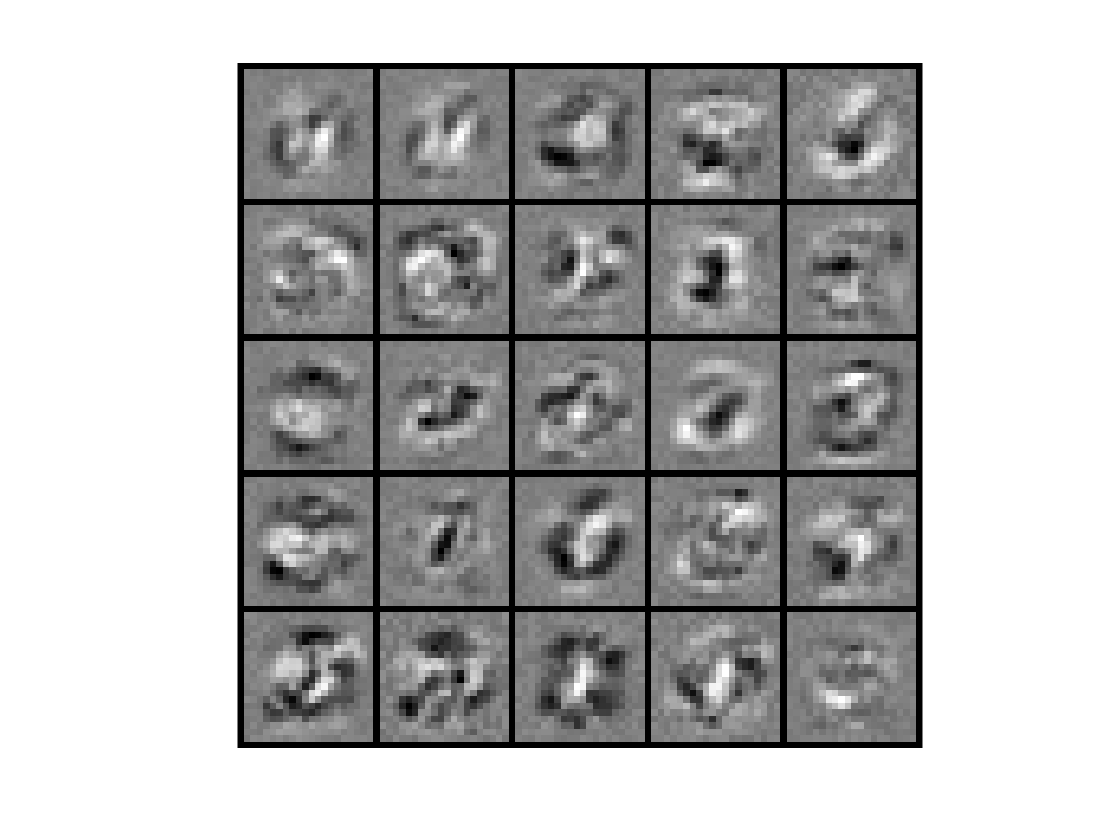


% Now, costFunction is a function that takes in only one argument (the
% neural network parameters)
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);
% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 

pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

## 3. Visualizing the hidden layer

One way to understand what your neural network is learning is to visualize what the representations captured by the hidden units. Informally, given a particular hidden unit, one way to visualize what it computes is to find an input `x` that will cause it to activate (that is, to have an activation value $(a^{(l)}_i)$close to 1). For the neural network you trained, notice that the $i^{th}$ row of $\Theta^{(1)}$ is a 401-dimensional vector that represents the parameter for the $i^{th}$ hidden unit. If we discard the bias term, we get a 400 dimensional vector that represents the weights from each input pixel to the hidden unit. 

    Thus, one way to visualize the 'representation' captured by the hidden unit is to reshape this 400 dimensional vector into a 20 x 20 image and display it.* 

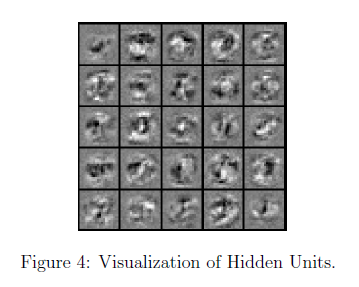

The code below does this by using the `displayData` function and it will show you an image (similar to Figure 4) with 25 units, each corresponding to one hidden unit in the network. In your trained network, you should find that the hidden units corresponds roughly to detectors that look for strokes and other patterns in the input.

% Visualize Weights 
displayData(Theta1(:, 2:end));

**It turns out that this is equivalent to finding the input that gives the highest activation for the hidden unit, given a 'norm' constraint on the input (i.e., *${\left\|x\right\|}_2 \le \;1$*).*

### 3.1 Optional (ungraded) exercise

In this part of the exercise, you will get to try out different learning settings for the neural network to see how the performance of the neural network varies with the regularization parameter and number of training steps (the `MaxIter` option when using `fmincg`). Neural networks are very powerful models that can form highly complex decision boundaries. Without regularization, it is possible for a neural network to 'overfit' a training set so that it obtains close to 100% accuracy on the training set but does not do as well on new examples that it has not seen before. You can set the regularization $\lambda$ to a smaller value and the `MaxIter` parameter to a higher number of iterations to see this for youself. You will also be able to see for yourself the changes in the visualizations of the hidden units when you change the learning parameters $\lambda$ and `MaxIter`.

% Change lambda and MaxIter to see how it affects the result

z2 =     0.4241    0.3134    0.7758    1.0492   -0.0600   -0.0531    0.2409    0.6022    0.8709    0.5424    0.5789    0.1378    0.9698    0.4798    0.4742    0.2161    0.7226    0.6409   -0.0533    1.2262    0.6489   -0.1140    0.4500    0.0237    0.2724    0.3863    0.7389    0.3812    0.1258    0.4611    0.1438    0.4277    0.5809    0.5335    0.9900    0.8658    0.6187    0.4091    0.9286    0.8900    0.4428    0.1801    0.3867    1.1604    0.3914    0.0976    0.6471    0.9565    0.5198    0.1741
    0.1932   -0.5614   -0.0582    0.2839    0.1807    0.6172    0.1551    0.1862    0.3836    0.3545    0.4005    0.3096    0.4429    0.3716    0.1925   -0.1959   -0.2028    0.1275   -0.2629    0.4406    0.1958    0.3994    0.3634    0.2364    0.4636    0.6171    0.2112   -0.0409    0.5050    0.3631    0.1173    0.0884    0.2221   -0.1442    0.2488   -0.0552    0.2470    0.5331    0.1462   -0.0550    0.2529    0.1911    0.3815   -0.2001   -0.1370    0.4056    0.0700    0.2357   -0.2333   -

a2 =     1.0000    0.6045    0.5481    0.4773    0.5073    0.6098    0.5313    0.4152    0.5296    0.3888    0.4965    0.6727    0.2955    0.5378    0.5744    0.4624    0.5431    0.3542    0.6607    0.6632    0.4088    0.4092    0.4201    0.4082    0.3532    0.6628
    1.0000    0.5777    0.3632    0.4984    0.4544    0.6688    0.6294    0.3222    0.5922    0.4279    0.4559    0.7508    0.3177    0.5377    0.5274    0.4813    0.5458    0.3444    0.7072    0.7003    0.3563    0.4282    0.3534    0.4728    0.4103    0.6681
    1.0000    0.6848    0.4854    0.3114    0.4783    0.5335    0.4621    0.3533    0.6402    0.4021    0.3813    0.6857    0.4425    0.5045    0.5508    0.4729    0.5329    0.3694    0.6151    0.6492    0.5929    0.4862    0.2854    0.2715    0.4103    0.4665
    1.0000    0.7406    0.5705    0.4232    0.4136    0.6043    0.4294    0.3555    0.5825    0.4248    0.4454    0.6732    0.3205    0.5246    0.5466    0.4497    0.5567    0.4406    0.6111    0.6052    0.4033  

z2 =     0.3944    0.2806    0.7406    1.0134   -0.0968   -0.0863    0.2020    0.5862    0.8323    0.5100    0.5442    0.1104    0.9334    0.4606    0.4416    0.1931    0.6849    0.6079   -0.0757    1.1900    0.6193   -0.1409    0.4206    0.0079    0.2490    0.3584    0.7223    0.3558    0.1116    0.4359    0.1316    0.3942    0.5424    0.5053    0.9516    0.8336    0.5918    0.3788    0.8886    0.8465    0.4085    0.1500    0.3549    1.1259    0.3646    0.0651    0.6125    0.9273    0.4924    0.1538
    0.1798   -0.5764   -0.0719    0.2695    0.1637    0.6025    0.1380    0.1794    0.3679    0.3401    0.3858    0.2977    0.4280    0.3638    0.1774   -0.2058   -0.2199    0.1136   -0.2733    0.4259    0.1838    0.3870    0.3506    0.2297    0.4544    0.6046    0.2055   -0.0513    0.4988    0.3520    0.1120    0.0746    0.2062   -0.1558    0.2325   -0.0680    0.2352    0.5192    0.1296   -0.0729    0.2381    0.1779    0.3687   -0.2137   -0.1490    0.3916    0.0548    0.2240   -0.2454   -

a2 =     1.0000    0.5973    0.5448    0.4722    0.4967    0.6168    0.5504    0.4163    0.5194    0.3876    0.4767    0.6621    0.2988    0.5631    0.5806    0.4565    0.5460    0.3577    0.6462    0.6575    0.4025    0.4227    0.4127    0.4037    0.3457    0.6676
    1.0000    0.5697    0.3598    0.4931    0.4430    0.6758    0.6486    0.3232    0.5815    0.4265    0.4346    0.7409    0.3215    0.5651    0.5342    0.4749    0.5489    0.3481    0.6929    0.6944    0.3498    0.4431    0.3460    0.4678    0.4016    0.6732
    1.0000    0.6771    0.4820    0.3064    0.4646    0.5426    0.4863    0.3544    0.6279    0.4000    0.3569    0.6725    0.4468    0.5376    0.5580    0.4653    0.5368    0.3740    0.5961    0.6414    0.5850    0.5042    0.2772    0.2672    0.3998    0.4741
    1.0000    0.7337    0.5670    0.4174    0.4006    0.6131    0.4530    0.3566    0.5698    0.4228    0.4205    0.6601    0.3245    0.5569    0.5539    0.4422    0.5607    0.4454    0.5921    0.5973    0.3955  

z2 =     0.3348    0.2152    0.6704    0.9418   -0.1706   -0.1528    0.1242    0.5541    0.7553    0.4452    0.4747    0.0555    0.8608    0.4222    0.3762    0.1470    0.6094    0.5418   -0.1205    1.1176    0.5603   -0.1947    0.3617   -0.0236    0.2023    0.3025    0.6892    0.3051    0.0830    0.3856    0.1071    0.3273    0.4653    0.4490    0.8748    0.7693    0.5380    0.3181    0.8086    0.7595    0.3399    0.0898    0.2912    1.0570    0.3109   -0.0001    0.5431    0.8689    0.4377    0.1132
    0.1531   -0.6065   -0.0992    0.2406    0.1299    0.5730    0.1039    0.1659    0.3366    0.3114    0.3563    0.2740    0.3982    0.3483    0.1471   -0.2256   -0.2541    0.0857   -0.2941    0.3964    0.1600    0.3622    0.3250    0.2164    0.4360    0.5794    0.1940   -0.0723    0.4865    0.3300    0.1014    0.0468    0.1745   -0.1790    0.1999   -0.0935    0.2116    0.4915    0.0962   -0.1088    0.2085    0.1516    0.3430   -0.2408   -0.1731    0.3635    0.0244    0.2006   -0.2695   -

a2 =     1.0000    0.5829    0.5382    0.4621    0.4756    0.6308    0.5881    0.4186    0.4991    0.3850    0.4372    0.6404    0.3054    0.6125    0.5929    0.4447    0.5518    0.3647    0.6163    0.6458    0.3900    0.4499    0.3981    0.3948    0.3308    0.6770
    1.0000    0.5536    0.3529    0.4824    0.4205    0.6897    0.6857    0.3252    0.5598    0.4236    0.3926    0.7206    0.3290    0.6188    0.5476    0.4620    0.5550    0.3554    0.6630    0.6824    0.3371    0.4732    0.3313    0.4578    0.3842    0.6834
    1.0000    0.6616    0.4752    0.2966    0.4374    0.5608    0.5348    0.3564    0.6027    0.3958    0.3105    0.6454    0.4554    0.6026    0.5722    0.4500    0.5448    0.3832    0.5571    0.6255    0.5691    0.5402    0.2613    0.2589    0.3791    0.4892
    1.0000    0.7195    0.5599    0.4058    0.3750    0.6303    0.5009    0.3589    0.5441    0.4189    0.3721    0.6332    0.3326    0.6198    0.5686    0.4275    0.5685    0.4551    0.5532    0.5814    0.3801  

z2 =     0.1660    0.0297    0.4714    0.7390   -0.3795   -0.3413   -0.0961    0.4633    0.5371    0.2618    0.2781   -0.1000    0.6549    0.3133    0.1911    0.0166    0.3956    0.3548   -0.2474    0.9126    0.3930   -0.3473    0.1948   -0.1128    0.0699    0.1441    0.5952    0.1614    0.0023    0.2430    0.0379    0.1378    0.2470    0.2894    0.6573    0.5872    0.3856    0.1462    0.5818    0.5129    0.1457   -0.0809    0.1108    0.8617    0.1591   -0.1847    0.3466    0.7034    0.2826   -0.0020
    0.0774   -0.6916   -0.1767    0.1588    0.0339    0.4896    0.0071    0.1276    0.2479    0.2301    0.2728    0.2069    0.3137    0.3042    0.0613   -0.2818   -0.3510    0.0067   -0.3530    0.3128    0.0925    0.2921    0.2526    0.1786    0.3837    0.5081    0.1614   -0.1315    0.4514    0.2674    0.0712   -0.0318    0.0846   -0.2448    0.1074   -0.1659    0.1447    0.4131    0.0017   -0.2105    0.1247    0.0771    0.2703   -0.3176   -0.2413    0.2839   -0.0617    0.1344   -0.3378   -

a2 =     1.0000    0.5414    0.5193    0.4336    0.4164    0.6692    0.6882    0.4250    0.4416    0.3778    0.3311    0.5762    0.3246    0.7382    0.6270    0.4116    0.5682    0.3848    0.5277    0.6120    0.3553    0.5283    0.3577    0.3698    0.2907    0.7030
    1.0000    0.5074    0.3337    0.4523    0.3588    0.7270    0.7778    0.3310    0.4974    0.4156    0.2836    0.6579    0.3508    0.7529    0.5854    0.4258    0.5723    0.3767    0.5717    0.6473    0.3021    0.5589    0.2915    0.4298    0.3366    0.7112
    1.0000    0.6157    0.4559    0.2698    0.3628    0.6114    0.6659    0.3622    0.5287    0.3840    0.1994    0.5639    0.4798    0.7629    0.6117    0.4074    0.5671    0.4097    0.4444    0.5791    0.5233    0.6389    0.2196    0.2361    0.3228    0.5323
    1.0000    0.6768    0.5396    0.3735    0.3066    0.6773    0.6336    0.3652    0.4704    0.4078    0.2503    0.5527    0.3559    0.7731    0.6094    0.3865    0.5904    0.4825    0.4411    0.5356    0.3378  

Iteration     1 | Cost: 3.323065e+00


z2 =    17.6155   18.6535   25.7393   24.0993   22.3456   20.4027   24.5429    9.1432   28.0360   20.9294   24.2594   16.0356   25.5018   11.1214   19.4357   14.1483   22.1270   18.9586   12.6460   26.2414   18.9055   15.3775   16.5975   10.3212   17.5036   16.5804   13.3441   16.7339    8.5302   14.6598    6.9364   18.8684   23.6079   17.0244   23.7079   22.5634   17.4116   17.9495   24.7344   27.3101   19.2995   16.9349   19.3808   24.9044   15.2235   18.8943   20.1055   17.0379   16.0325   12.2436
   15.8713   15.9720   22.9606   21.8893   19.9407   18.9718   21.9473    8.4830   25.0082   18.5492   21.6535   15.1201   22.9541   10.7872   17.0091   12.6702   19.2670   17.6875   11.0929   23.2597   17.6553   14.2302   15.6277    9.6080   16.0944   15.2550   12.2331   15.1764    8.2343   13.5513    6.4454   18.0561   22.2080   15.6812   21.6120   20.1949   15.4477   16.3228   22.7025   24.9617   18.1864   15.9463   18.5548   21.8656   13.5811   18.0162   18.2065   16.1537   14.1969   1

a2 =     1.0000    1.0000    1.0000    0.9997    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9992    1.0000    1.0000
    1.0000    1.0000    1.0000    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9997    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000  

z2 =     4.3685    4.5150    6.5568    6.3650    5.0935    4.6546    5.8378    2.5537    7.1598    5.2393    6.0536    3.7860    6.6389    2.9163    4.8259    3.4200    5.6293    4.8352    2.8578    7.0127    4.8514    3.4398    4.1451    2.4001    4.2685    4.1025    3.6656    4.1526    2.0561    3.7150    1.6993    4.6488    5.8731    4.3198    6.2087    5.8798    4.4860    4.4339    6.3986    6.9666    4.7586    4.0171    4.7517    6.6520    3.7871    4.4102    5.1053    4.6373    4.0758    2.9472
    3.8811    3.3216    5.3956    5.3923    4.8281    4.9408    5.2911    2.1399    6.2111    4.6420    5.4220    3.7985    5.7663    2.8289    4.1429    2.8375    4.3737    4.2649    2.4036    5.8393    4.3223    3.6489    3.9554    2.4496    4.1674    4.0597    3.0687    3.5552    2.3258    3.4666    1.6063    4.3244    5.4127    3.5908    5.2865    4.7377    3.8302    4.2447    5.4688    5.8518    4.4746    3.8990    4.6738    5.0249    3.0876    4.5545    4.3379    3.9924    3.1627    

a2 =     1.0000    0.9875    0.9798    0.8528    0.9592    0.9966    0.9909    0.9673    0.9796    0.9535    0.9030    0.9872    0.9465    0.9849    0.9962    0.9473    0.9826    0.8971    0.9391    0.9925    0.9283    0.9736    0.8875    0.7878    0.9296    0.9886
    1.0000    0.9892    0.9652    0.8963    0.9616    0.9981    0.9958    0.9610    0.9883    0.9701    0.9045    0.9935    0.9650    0.9895    0.9968    0.9619    0.9865    0.9082    0.9662    0.9956    0.9314    0.9835    0.8845    0.8543    0.9536    0.9918
    1.0000    0.9986    0.9955    0.8985    0.9812    0.9985    0.9948    0.9797    0.9951    0.9766    0.9046    0.9970    0.9812    0.9944    0.9979    0.9794    0.9947    0.9517    0.9779    0.9970    0.9884    0.9935    0.8833    0.8408    0.9757    0.9944
    1.0000    0.9983    0.9955    0.9131    0.9716    0.9989    0.9944    0.9798    0.9929    0.9785    0.9284    0.9963    0.9733    0.9944    0.9982    0.9751    0.9948    0.9632    0.9675    0.9964    0.9689  

z2 =     1.2024    1.1359    1.9721    2.1265    0.9702    0.8908    1.3673    0.9788    2.1704    1.4893    1.7024    0.8583    2.1306    0.9552    1.3341    0.8559    1.6863    1.4597    0.5184    2.4170    1.4925    0.5867    1.1690    0.5069    1.1053    1.1203    1.3524    1.1457    0.5088    1.0992    0.4477    1.2503    1.6345    1.2834    2.0264    1.8924    1.3968    1.2036    2.0163    2.1045    1.2833    0.9297    1.2553    2.2897    1.0538    0.9485    1.5202    1.6736    1.2181    0.7253
    1.0154    0.2981    1.1975    1.4494    1.2162    1.5873    1.3102    0.6239    1.7185    1.3181    1.5426    1.0927    1.6584    0.9268    1.0679    0.4875    0.8142    1.0568    0.3268    1.6757    1.1356    1.1200    1.1658    0.7387    1.3168    1.3840    0.8784    0.7777    0.9137    1.0564    0.4498    1.0425    1.3986    0.7012    1.3847    1.0434    1.0536    1.3580    1.3500    1.2845    1.1974    1.0197    1.3563    0.9999    0.5796    1.3371    1.0233    1.0858    0.5255    

a2 =     1.0000    0.7690    0.7341    0.5577    0.6282    0.8736    0.8523    0.6474    0.6852    0.5912    0.5051    0.7864    0.5391    0.8595    0.8541    0.6090    0.7688    0.5450    0.6809    0.8246    0.5455    0.7261    0.5171    0.4805    0.4912    0.8520
    1.0000    0.7569    0.5740    0.5957    0.5883    0.9079    0.9082    0.5646    0.7477    0.6460    0.4642    0.8497    0.5876    0.8765    0.8426    0.6389    0.7822    0.5463    0.7397    0.8572    0.5032    0.7660    0.4584    0.5556    0.5584    0.8655
    1.0000    0.8778    0.7681    0.4471    0.6345    0.8749    0.8602    0.6293    0.8019    0.6373    0.3793    0.8357    0.7138    0.8962    0.8661    0.6615    0.8165    0.6130    0.6828    0.8423    0.7624    0.8417    0.3879    0.3836    0.5873    0.7985
    1.0000    0.8934    0.8099    0.5475    0.5639    0.9030    0.8443    0.6319    0.7554    0.6594    0.4515    0.8232    0.6083    0.9005    0.8696    0.6356    0.8280    0.6797    0.6589    0.8165    0.5845  

z2 =     0.6758    0.5738    1.2096    1.4215    0.2844    0.2648    0.6237    0.7168    1.3405    0.8656    0.9787    0.3714    1.3808    0.6291    0.7533    0.4295    1.0305    0.8983    0.1293    1.6526    0.9338    0.1122    0.6740    0.1920    0.5792    0.6243    0.9676    0.6455    0.2514    0.6642    0.2395    0.6851    0.9295    0.7784    1.3308    1.2292    0.8830    0.6663    1.2875    1.2958    0.7053    0.4162    0.6738    1.5641    0.5992    0.3727    0.9239    1.1806    0.7428    0.3558
    0.5388   -0.2048    0.4993    0.7937    0.6155    1.0296    0.6481    0.3717    0.9713    0.7653    0.8974    0.6426    0.9751    0.6104    0.5564    0.0966    0.2221    0.5233   -0.0186    0.9832    0.6056    0.6993    0.7018    0.4541    0.8427    0.9390    0.5141    0.3157    0.6788    0.6555    0.2575    0.4966    0.7309    0.2205    0.7357    0.4289    0.5918    0.8779    0.6649    0.5249    0.6524    0.5408    0.8045    0.3305    0.1625    0.8020    0.4720    0.6024    0.0868   -

a2 =     1.0000    0.6628    0.6315    0.4946    0.5216    0.7873    0.7798    0.5363    0.5655    0.4820    0.4141    0.6894    0.4267    0.8050    0.7564    0.5091    0.6749    0.4627    0.6057    0.7297    0.4470    0.6312    0.4344    0.4233    0.3845    0.7856
    1.0000    0.6397    0.4490    0.5233    0.4702    0.8353    0.8537    0.4428    0.6292    0.5306    0.3679    0.7657    0.4654    0.8221    0.7311    0.5322    0.6850    0.4590    0.6594    0.7668    0.3967    0.6690    0.3698    0.4915    0.4429    0.7980
    1.0000    0.7702    0.6223    0.3520    0.4963    0.7662    0.7763    0.4932    0.6784    0.5093    0.2792    0.7172    0.6007    0.8395    0.7594    0.5347    0.7050    0.5102    0.5656    0.7284    0.6504    0.7524    0.2955    0.3037    0.4494    0.6776
    1.0000    0.8056    0.6886    0.4578    0.4284    0.8137    0.7521    0.4962    0.6212    0.5338    0.3423    0.7035    0.4788    0.8464    0.7612    0.5098    0.7229    0.5829    0.5507    0.6914    0.4566  

Iteration     2 | Cost: 3.259157e+00


z2 =     0.4706    0.2799    1.6075    1.5186    0.1647    0.1944    0.6089    0.5303    1.7374    0.8763    1.2223    0.1966    1.6096    0.4581    0.5313    0.3557    0.7307    0.5881   -0.0605    1.9620    0.9114   -0.0933    0.3706    0.2416    0.9197    0.4408    1.2742    0.7102    0.1794    0.4525    0.1296    0.3636    0.7900    0.6396    1.1572    1.4361    0.8613    0.4593    1.1341    1.1941    0.3591    0.1309    0.5568    1.8569    0.3417    0.1567    0.6180    0.9101    0.5284    0.2700
    0.3432   -0.5279    0.9088    0.9785    0.4041    0.9402    0.5668    0.3066    1.3250    0.6873    1.0612    0.5696    1.2195    0.6045    0.2786    0.0710   -0.0779    0.4212   -0.2266    1.2680    0.7459    0.4847    0.5492    0.5142    1.1690    0.7737    0.9078    0.4487    0.6489    0.5304    0.1820    0.4483    0.8109    0.2483    0.7008    0.7198    0.5598    0.6568    0.6765    0.6079    0.5002    0.3870    0.8839    0.6827   -0.0459    0.7315    0.2775    0.6108   -0.0605   -

a2 =     1.0000    0.6155    0.5850    0.2386    0.5813    0.8860    0.8399    0.7215    0.6428    0.5950    0.4312    0.5674    0.5405    0.7867    0.9129    0.4113    0.6213    0.5022    0.3345    0.7958    0.3389    0.5397    0.4032    0.2069    0.4032    0.7283
    1.0000    0.5695    0.3710    0.2761    0.5438    0.9137    0.8999    0.6344    0.7060    0.6521    0.3859    0.6486    0.5979    0.8077    0.9049    0.4293    0.6123    0.4886    0.4229    0.8337    0.2937    0.5901    0.3523    0.2508    0.4508    0.7343
    1.0000    0.8331    0.7128    0.1946    0.5928    0.8639    0.8004    0.6751    0.7548    0.5782    0.2710    0.6427    0.5987    0.8228    0.8813    0.4361    0.6755    0.5513    0.3700    0.7784    0.5970    0.6584    0.2461    0.1612    0.4781    0.6532
    1.0000    0.8203    0.7268    0.2244    0.4996    0.9021    0.7989    0.6928    0.6936    0.6189    0.3584    0.6193    0.5366    0.8325    0.9048    0.4063    0.7001    0.6345    0.2916    0.7595    0.3619  

z2 =     0.6198    0.4935    1.3183    1.4480    0.2517    0.2455    0.6197    0.6659    1.4489    0.8685    1.0453    0.3236    1.4433    0.5824    0.6927    0.4093    0.9486    0.8136    0.0775    1.7371    0.9277    0.0560    0.5911    0.2055    0.6722    0.5742    1.0514    0.6632    0.2317    0.6063    0.2095    0.5973    0.8914    0.7405    1.2834    1.2857    0.8771    0.6098    1.2456    1.2681    0.6107    0.3383    0.6418    1.6441    0.5289    0.3137    0.8403    1.1067    0.6842    0.3323
    0.4854   -0.2930    0.6111    0.8442    0.5577    1.0052    0.6259    0.3539    1.0679    0.7440    0.9422    0.6227    1.0419    0.6088    0.4805    0.0896    0.1402    0.4954   -0.0754    1.0610    0.6439    0.6407    0.6601    0.4705    0.9318    0.8938    0.6216    0.3520    0.6706    0.6213    0.2368    0.4834    0.7528    0.2281    0.7262    0.5084    0.5831    0.8175    0.6681    0.5476    0.6108    0.4988    0.8262    0.4267    0.1056    0.7828    0.4189    0.6047    0.0466   -

a2 =     1.0000    0.6502    0.6190    0.4176    0.5381    0.8193    0.7977    0.5904    0.5871    0.5132    0.4187    0.6578    0.4576    0.8001    0.8123    0.4821    0.6607    0.4734    0.5310    0.7490    0.4165    0.6068    0.4258    0.3563    0.3895    0.7709
    1.0000    0.6209    0.4273    0.4513    0.4903    0.8611    0.8679    0.4959    0.6511    0.5648    0.3727    0.7366    0.5019    0.8182    0.7929    0.5040    0.6659    0.4671    0.5975    0.7868    0.3672    0.6481    0.3650    0.4198    0.4451    0.7818
    1.0000    0.7889    0.6482    0.3033    0.5230    0.7970    0.7830    0.5449    0.7005    0.5283    0.2769    0.6978    0.6002    0.8351    0.7994    0.5077    0.6971    0.5214    0.5116    0.7427    0.6361    0.7285    0.2815    0.2585    0.4573    0.6711
    1.0000    0.8097    0.6993    0.3866    0.4477    0.8426    0.7656    0.5526    0.6417    0.5575    0.3467    0.6816    0.4946    0.8427    0.8112    0.4812    0.7168    0.5972    0.4764    0.7111    0.4301  

Iteration     3 | Cost: 3.235400e+00


z2 =     0.5404    0.3811    1.4303    1.4628    0.1969    0.2080    0.5970    0.6033    1.5622    0.8577    1.1105    0.2608    1.5044    0.5231    0.6039    0.3802    0.8337    0.7088    0.0054    1.8237    0.9131   -0.0189    0.4882    0.2178    0.7766    0.5039    1.1457    0.6775    0.2066    0.5310    0.1638    0.4887    0.8409    0.6865    1.2183    1.3426    0.8605    0.5333    1.1846    1.2207    0.4929    0.2388    0.5971    1.7214    0.4374    0.2405    0.7265    1.0118    0.6043    0.2947
    0.4390   -0.3832    0.7577    0.9183    0.5175    0.9991    0.6202    0.3416    1.2083    0.7367    1.0199    0.6196    1.1461    0.6166    0.4125    0.0994    0.0626    0.4845   -0.1274    1.1756    0.7101    0.5921    0.6318    0.5033    1.0585    0.8597    0.7603    0.4150    0.6728    0.5980    0.2142    0.4917    0.8089    0.2533    0.7422    0.6245    0.5934    0.7689    0.6950    0.5999    0.5872    0.4710    0.8701    0.5584    0.0556    0.7892    0.3757    0.6210    0.0149   -

a2 =     1.0000    0.6319    0.6080    0.3427    0.5541    0.8503    0.8180    0.6440    0.5975    0.5537    0.4243    0.6295    0.4986    0.7982    0.8596    0.4591    0.6505    0.4953    0.4492    0.7689    0.3871    0.5935    0.4178    0.2947    0.3965    0.7654
    1.0000    0.5941    0.4053    0.3830    0.5112    0.8854    0.8834    0.5486    0.6609    0.6083    0.3792    0.7092    0.5500    0.8175    0.8449    0.4801    0.6495    0.4870    0.5302    0.8075    0.3397    0.6396    0.3620    0.3534    0.4496    0.7745
    1.0000    0.8070    0.6809    0.2651    0.5510    0.8250    0.7900    0.5922    0.7081    0.5525    0.2756    0.6855    0.6053    0.8331    0.8295    0.4877    0.6959    0.5430    0.4558    0.7521    0.6281    0.7149    0.2690    0.2229    0.4708    0.6784
    1.0000    0.8120    0.7147    0.3223    0.4660    0.8690    0.7803    0.6060    0.6461    0.5879    0.3531    0.6671    0.5183    0.8415    0.8504    0.4589    0.7172    0.6224    0.3974    0.7265    0.4071  

z2 =     0.3817    0.1561    1.6544    1.4923    0.0872    0.1328    0.5517    0.4783    1.7889    0.8359    1.2411    0.1351    1.6264    0.4046    0.4262    0.3221    0.6039    0.4992   -0.1389    1.9968    0.8838   -0.1689    0.2823    0.2423    0.9852    0.3633    1.3344    0.7062    0.1563    0.3803    0.0726    0.2716    0.7398    0.5785    1.0882    1.4565    0.8275    0.3802    1.0626    1.1261    0.2573    0.0396    0.5078    1.8759    0.2545    0.0941    0.4988    0.8218    0.4443    0.2193
    0.3461   -0.5636    1.0508    1.0665    0.4372    0.9869    0.6089    0.3168    1.4891    0.7221    1.1753    0.6134    1.3547    0.6321    0.2765    0.1188   -0.0926    0.4627   -0.2314    1.4046    0.8424    0.4948    0.5753    0.5689    1.3119    0.7914    1.0375    0.5411    0.6772    0.5512    0.1691    0.5082    0.9212    0.3036    0.7743    0.8568    0.6141    0.6717    0.7490    0.7046    0.5401    0.4154    0.9580    0.8219   -0.0443    0.8020    0.2895    0.6537   -0.0484   -

a2 =     1.0000    0.5943    0.5857    0.2161    0.5856    0.8991    0.8538    0.7402    0.6180    0.6320    0.4355    0.5702    0.5801    0.7945    0.9245    0.4136    0.6297    0.5391    0.2974    0.8054    0.3309    0.5666    0.4017    0.1924    0.4106    0.7543
    1.0000    0.5389    0.3627    0.2613    0.5528    0.9232    0.9098    0.6497    0.6801    0.6899    0.3923    0.6499    0.6427    0.8162    0.9170    0.4328    0.6158    0.5269    0.3949    0.8443    0.2880    0.6223    0.3562    0.2377    0.4587    0.7592
    1.0000    0.8395    0.7409    0.1984    0.6059    0.8718    0.8034    0.6811    0.7231    0.6000    0.2728    0.6602    0.6156    0.8291    0.8787    0.4478    0.6933    0.5856    0.3486    0.7702    0.6120    0.6866    0.2452    0.1625    0.4980    0.6928
    1.0000    0.8164    0.7439    0.2130    0.5027    0.9105    0.8076    0.7046    0.6550    0.6465    0.3660    0.6371    0.5653    0.8391    0.9088    0.4148    0.7179    0.6709    0.2572    0.7558    0.3623  

z2 =    -0.0943   -0.5189    2.3267    1.5810   -0.2418   -0.0926    0.4159    0.1030    2.4687    0.7706    1.6328   -0.2420    1.9926    0.0489   -0.1067    0.1477   -0.0856   -0.1296   -0.5715    2.5161    0.7961   -0.6186   -0.3355    0.3158    1.6112   -0.0585    1.9005    0.7923    0.0055   -0.0719   -0.2012   -0.3797    0.4366    0.2546    0.6978    1.7982    0.7283   -0.0788    0.6966    0.8423   -0.4494   -0.5577    0.2398    2.3395   -0.2943   -0.3450   -0.1842    0.2520   -0.0355   -0.0067
    0.0676   -1.1047    1.9302    1.5111    0.1961    0.9504    0.5749    0.2425    2.3316    0.6783    1.6415    0.5950    1.9803    0.6787   -0.1316    0.1773   -0.5581    0.3973   -0.5433    2.0918    1.2393    0.2030    0.4057    0.7658    2.0720    0.5864    1.8693    0.9192    0.6902    0.4110    0.0335    0.5578    1.2579    0.4547    0.8706    1.5536    0.6760    0.3800    0.9109    1.0186    0.3986    0.2487    1.2216    1.6122   -0.3441    0.8406    0.0307    0.7517   -0.2384   -

a2 =     1.0000    0.4764    0.5169    0.0392    0.6754    0.9718    0.9275    0.9175    0.6768    0.8201    0.4694    0.3872    0.7874    0.7829    0.9899    0.2881    0.5647    0.6643    0.0559    0.8883    0.1919    0.4839    0.3550    0.0423    0.4536    0.7186
    1.0000    0.3731    0.2489    0.0614    0.6712    0.9783    0.9596    0.8683    0.7340    0.8674    0.4325    0.4501    0.8514    0.8120    0.9892    0.3010    0.5091    0.6426    0.1120    0.9214    0.1643    0.5685    0.3388    0.0548    0.4860    0.7093
    1.0000    0.9111    0.8733    0.0741    0.7514    0.9533    0.8396    0.8718    0.7651    0.7291    0.2647    0.5791    0.6456    0.8167    0.9599    0.3338    0.6856    0.7040    0.1226    0.8188    0.5622    0.5935    0.1825    0.0567    0.5791    0.7337
    1.0000    0.8293    0.8192    0.0476    0.6113    0.9735    0.8740    0.8989    0.6810    0.7940    0.4060    0.5415    0.6966    0.8316    0.9817    0.2928    0.7202    0.7940    0.0477    0.8303    0.2437  

z2 =    -0.6816   -1.3515    3.1561    1.6904   -0.6477   -0.3706    0.2482   -0.3600    3.3074    0.6901    2.1159   -0.7071    2.4443   -0.3898   -0.7641   -0.0675   -0.9361   -0.9052   -1.1053    3.1568    0.6879   -1.1735   -1.0976    0.4064    2.3835   -0.5788    2.5988    0.8984   -0.1805   -0.6298   -0.5389   -1.1831    0.0626   -0.1450    0.2162    2.2196    0.6060   -0.6452    0.2452    0.4922   -1.3213   -1.2946   -0.0909    2.9115   -0.9712   -0.8867   -1.0268   -0.4510   -0.6274   -0.2856
   -0.2761   -1.7723    3.0151    2.0596   -0.1013    0.9054    0.5329    0.1509    3.3709    0.6243    2.2166    0.5722    2.7521    0.7362   -0.6351    0.2493   -1.1324    0.3167   -0.9281    2.9395    1.7289   -0.1571    0.1964    1.0086    3.0096    0.3336    2.8954    1.3856    0.7063    0.2381   -0.1337    0.6189    1.6734    0.6410    0.9894    2.4132    0.7525    0.0202    1.1106    1.4059    0.2241    0.0430    1.5469    2.5872   -0.7139    0.8881   -0.2885    0.8726   -0.4728   -

a2 =     1.0000    0.3359    0.4314    0.0038    0.7703    0.9945    0.9712    0.9835    0.7423    0.9383    0.5116    0.2020    0.9260    0.7680    0.9992    0.1694    0.4817    0.7910    0.0052    0.9469    0.0876    0.3835    0.3011    0.0055    0.5076    0.6705
    1.0000    0.2056    0.1453    0.0081    0.7912    0.9957    0.9856    0.9692    0.7920    0.9611    0.4832    0.2296    0.9599    0.8067    0.9992    0.1753    0.3773    0.7645    0.0163    0.9681    0.0747    0.5001    0.3180    0.0072    0.5199    0.6401
    1.0000    0.9591    0.9533    0.0195    0.8743    0.9876    0.8766    0.9659    0.8105    0.8470    0.2549    0.4734    0.6811    0.8004    0.9905    0.2168    0.6759    0.8188    0.0259    0.8673    0.4991    0.4695    0.1233    0.0140    0.6732    0.7791
    1.0000    0.8443    0.8869    0.0062    0.7307    0.9944    0.9280    0.9783    0.7115    0.9063    0.4571    0.4200    0.8224    0.8220    0.9977    0.1758    0.7230    0.8942    0.0046    0.8960    0.1379  

Iteration     4 | Cost: 2.776094e+00


z2 =    -2.4657   -3.7755    4.9815    1.6718   -2.0621   -1.4176   -0.5278   -1.6553    5.0997    0.1994    3.0207   -2.1426    3.2635   -1.6528   -2.7779   -0.8399   -3.4528   -3.1581   -2.6963    4.4755    0.1485   -2.8603   -3.2885    0.4815    4.1328   -2.1679    4.2455    0.9447   -0.7841   -2.2767   -1.5170   -3.5155   -1.2320   -1.4062   -1.3577    3.0075    0.0238   -2.3805   -1.2525   -0.7890   -3.8476   -3.4567   -1.1970    4.0704   -2.9440   -2.5673   -3.5012   -2.4587   -2.3941   -1.1979
   -1.2881   -3.6198    5.5488    3.2503   -0.9958    0.6465    0.2387   -0.1603    5.8264    0.3411    3.5181    0.3969    4.5390    0.7805   -2.0347    0.3243   -2.7569   -0.0427   -1.9891    4.9116    2.8313   -1.1823   -0.4576    1.5521    5.2951   -0.4176    5.4089    2.4590    0.6855   -0.3099   -0.6248    0.6213    2.5571    0.9755    1.1196    4.4340    0.8302   -1.0076    1.4208    2.1724   -0.3647   -0.6098    2.2033    4.8878   -1.7620    0.8839   -1.2517    1.0299   -1.1925    

a2 =     1.0000    0.0783    0.2162    0.0000    0.8677    0.9999    0.9978    0.9997    0.8650    0.9961    0.4007    0.0147    0.9955    0.7583    1.0000    0.0247    0.1701    0.9340    0.0000    0.9954    0.0088    0.1359    0.1054    0.0000    0.5125    0.6697
    1.0000    0.0224    0.0261    0.0001    0.9113    0.9999    0.9991    0.9992    0.8930    0.9982    0.3782    0.0130    0.9986    0.8203    1.0000    0.0237    0.0706    0.9123    0.0002    0.9983    0.0077    0.2602    0.1505    0.0000    0.4765    0.5917
    1.0000    0.9932    0.9961    0.0008    0.9684    0.9996    0.9505    0.9987    0.8979    0.9616    0.0985    0.1322    0.7356    0.7988    0.9998    0.0399    0.4604    0.9306    0.0007    0.9675    0.3282    0.1475    0.0199    0.0003    0.8061    0.9094
    1.0000    0.8418    0.9627    0.0000    0.8485    0.9999    0.9870    0.9995    0.7835    0.9869    0.3443    0.0997    0.9577    0.8305    1.0000    0.0264    0.5503    0.9746    0.0000    0.9840    0.0240  

Iteration     5 | Cost: 2.495477e+00


z2 =    -3.2987   -4.8801    5.8954    1.7031   -2.7514   -1.9280   -0.8590   -2.2039    5.9454   -0.0061    3.4359   -2.8069    3.6395   -2.1916   -3.7429   -1.2213   -4.6129   -4.1623   -3.4468    5.1096   -0.1169   -3.6430   -4.2662    0.5038    4.9281   -2.8959    5.0228    0.9625   -1.0485   -3.0122   -1.9624   -4.5839   -1.8449   -1.9824   -2.0983    3.3810   -0.2787   -3.2017   -1.9399   -1.3837   -5.0083   -4.4669   -1.6717    4.6227   -3.8681   -3.3632   -4.6498   -3.3226   -3.2196   -1.6331
   -1.6234   -4.3131    6.8463    3.9324   -1.2281    0.6891    0.2880   -0.2166    7.1205    0.3621    4.2614    0.4467    5.5050    0.8934   -2.5049    0.4489   -3.3321   -0.0463   -2.3584    5.9701    3.4366   -1.5065   -0.6000    1.8680    6.4491   -0.6074    6.6158    3.0466    0.7517   -0.4224   -0.7878    0.7646    3.1102    1.2343    1.3353    5.4865    0.9771   -1.3293    1.7180    2.6927   -0.4746   -0.7713    2.6471    6.0819   -2.1256    1.0269   -1.5283    1.2448   -1.4124    

a2 =     1.0000    0.0356    0.1647    0.0000    0.8614    1.0000    0.9993    0.9999    0.9221    0.9987    0.3111    0.0032    0.9990    0.7886    1.0000    0.0093    0.1023    0.9389    0.0000    0.9986    0.0043    0.0769    0.0453    0.0000    0.2701    0.8685
    1.0000    0.0075    0.0132    0.0000    0.9149    1.0000    0.9998    0.9998    0.9379    0.9995    0.2743    0.0024    0.9998    0.8565    1.0000    0.0083    0.0322    0.9093    0.0000    0.9996    0.0039    0.1826    0.0707    0.0000    0.2208    0.8238
    1.0000    0.9973    0.9989    0.0002    0.9749    0.9999    0.9697    0.9997    0.9450    0.9753    0.0487    0.0457    0.7978    0.8446    1.0000    0.0165    0.4061    0.9058    0.0002    0.9852    0.3639    0.0801    0.0053    0.0000    0.7319    0.9788
    1.0000    0.8459    0.9808    0.0000    0.8325    1.0000    0.9944    0.9999    0.8567    0.9937    0.2643    0.0339    0.9830    0.8689    1.0000    0.0102    0.5005    0.9735    0.0000    0.9937    0.0160  

Iteration     6 | Cost: 2.275145e+00


z2 =    -5.0095   -7.0773    7.1573    1.4346   -4.3073   -3.1454   -1.7969   -3.2053    7.0256   -0.6753    3.7986   -4.1629    3.9271   -3.2026   -5.7266   -2.1022   -6.9599   -6.0871   -4.9337    5.8553   -0.8335   -5.2066   -6.1107    0.3851    6.0462   -4.3694    6.2230    0.7710   -1.5962   -4.4321   -2.8345   -6.6439   -3.2125   -3.1810   -3.7046    3.7458   -1.0816   -4.9028   -3.4645   -2.7885   -7.2386   -6.4421   -2.6978    5.2549   -5.6900   -4.9919   -6.9126   -4.9429   -4.8706   -2.5618
   -2.3872   -5.7114    8.7436    4.8070   -1.8334    0.5522    0.0976   -0.4112    9.0581    0.1812    5.2937    0.3693    6.8961    0.9546   -3.4778    0.5100   -4.5622   -0.2484   -3.1043    7.5140    4.2666   -2.2069   -0.9998    2.3042    8.2721   -1.0808    8.5382    3.8762    0.7779   -0.7527   -1.1534    0.8002    3.8047    1.4841    1.4580    7.0570    1.0603   -2.0433    1.9444    3.2744   -0.8592   -1.2258    3.1844    7.8699   -2.9009    1.0880   -2.2083    1.4222   -1.9675    

a2 =     1.0000    0.0066    0.0842    0.0000    0.7694    1.0000    0.9998    1.0000    0.9379    0.9998    0.4842    0.0002    1.0000    0.4861    1.0000    0.0020    0.0238    0.9590    0.0000    0.9994    0.0022    0.0411    0.0422    0.0000    0.1689    0.9735
    1.0000    0.0008    0.0033    0.0000    0.8671    1.0000    0.9999    1.0000    0.9428    0.9999    0.4308    0.0001    1.0000    0.6128    1.0000    0.0015    0.0046    0.9285    0.0000    0.9999    0.0022    0.1447    0.0819    0.0000    0.1391    0.9596
    1.0000    0.9992    0.9998    0.0001    0.9693    1.0000    0.9590    0.9999    0.9511    0.9886    0.1073    0.0052    0.9739    0.5330    1.0000    0.0045    0.2046    0.8710    0.0000    0.9788    0.5939    0.0481    0.0043    0.0000    0.9302    0.9963
    1.0000    0.8076    0.9919    0.0000    0.6740    1.0000    0.9960    1.0000    0.8387    0.9983    0.5956    0.0041    0.9992    0.5800    1.0000    0.0025    0.2708    0.9778    0.0000    0.9923    0.0147  

Iteration     7 | Cost: 2.031279e+00


z2 =    -6.6748   -9.0868    7.2658    0.5446   -6.0384   -4.6031   -3.1532   -4.0676    6.8940   -1.7662    3.2904   -5.5420    3.3313   -4.1313   -7.6202   -3.1412   -9.1713   -7.8572   -6.2774    5.5679   -1.8956   -6.6781   -7.7574   -0.0297    6.2182   -5.8146    6.6441    0.1352   -2.1781   -5.7482   -3.5991   -8.5408   -4.8306   -4.4626   -5.4797    3.3199   -2.1669   -6.5827   -5.1984   -4.5326   -9.2529   -8.2407   -3.9056    4.9422   -7.3398   -6.6474   -8.9859   -6.4335   -6.4091   -3.5255
   -3.2809   -7.0363    9.4138    4.8389   -2.7338   -0.0223   -0.5696   -0.7658    9.7263   -0.3689    5.4562   -0.0829    7.2438    0.7028   -4.5375    0.2156   -5.8612   -0.8560   -3.8854    7.9735    4.3521   -3.0371   -1.6743    2.3448    9.0787   -1.7771    9.4882    4.0208    0.5752   -1.3256   -1.5639    0.3177    3.6671    1.2275    0.9848    7.5744    0.7331   -2.9062    1.5118    3.0033   -1.6048   -1.9554    3.0464    8.4998   -3.7529    0.6432   -3.1343    1.0983   -2.7076    

a2 =     1.0000    0.0013    0.0362    0.0000    0.3191    1.0000    0.9998    1.0000    0.9004    0.9999    0.2500    0.0000    1.0000    0.1085    1.0000    0.0004    0.0018    0.9683    0.0000    0.9997    0.0005    0.0193    0.0089    0.0000    0.0174    0.9881
    1.0000    0.0001    0.0009    0.0000    0.4645    1.0000    0.9999    1.0000    0.8943    1.0000    0.1937    0.0000    1.0000    0.1662    1.0000    0.0003    0.0002    0.9389    0.0000    1.0000    0.0005    0.0896    0.0167    0.0000    0.0136    0.9798
    1.0000    0.9993    0.9999    0.0001    0.8093    1.0000    0.8719    0.9998    0.9088    0.9922    0.0413    0.0012    0.9931    0.1125    1.0000    0.0009    0.0175    0.8320    0.0000    0.9861    0.4239    0.0253    0.0005    0.0000    0.8619    0.9979
    1.0000    0.6329    0.9921    0.0000    0.1433    1.0000    0.9911    1.0000    0.6823    0.9992    0.3959    0.0010    0.9999    0.1175    1.0000    0.0004    0.0239    0.9794    0.0000    0.9953    0.0039  

z2 =    -5.8401   -8.0796    7.2114    0.9907   -5.1707   -3.8725   -2.4734   -3.6354    6.9600   -1.2194    3.5451   -4.8508    3.6299   -3.6658   -6.6711   -2.6204   -8.0629   -6.9700   -5.6039    5.7120   -1.3633   -5.9406   -6.9320    0.1782    6.1320   -5.0903    6.4331    0.4539   -1.8865   -5.0885   -3.2159   -7.5900   -4.0196   -3.8203   -4.5900    3.5334   -1.6229   -5.7407   -4.3293   -3.6584   -8.2433   -7.3392   -3.3002    5.0989   -6.5128   -5.8176   -7.9467   -5.6864   -5.6379   -3.0425
   -2.8330   -6.3722    9.0779    4.8229   -2.2825    0.2656   -0.2352   -0.5881    9.3914   -0.0932    5.3748    0.1438    7.0695    0.8290   -4.0064    0.3631   -5.2101   -0.5515   -3.4939    7.7432    4.3092   -2.6210   -1.3362    2.3244    8.6744   -1.4281    9.0121    3.9483    0.6768   -1.0384   -1.3582    0.5596    3.7361    1.3561    1.2220    7.3151    0.8971   -2.4737    1.7286    3.1392   -1.2311   -1.5897    3.1156    8.1841   -3.3258    0.8661   -2.6702    1.2607   -2.3366    

a2 =     1.0000    0.0029    0.0556    0.0000    0.5562    1.0000    0.9998    1.0000    0.9212    0.9999    0.3590    0.0001    1.0000    0.2538    1.0000    0.0009    0.0066    0.9639    0.0000    0.9996    0.0011    0.0282    0.0196    0.0000    0.0568    0.9822
    1.0000    0.0003    0.0017    0.0000    0.7046    1.0000    0.9999    1.0000    0.9220    1.0000    0.2993    0.0000    1.0000    0.3602    1.0000    0.0006    0.0010    0.9339    0.0000    0.9999    0.0011    0.1144    0.0375    0.0000    0.0452    0.9714
    1.0000    0.9993    0.9999    0.0001    0.9206    1.0000    0.9267    0.9998    0.9330    0.9906    0.0672    0.0025    0.9865    0.2761    1.0000    0.0020    0.0635    0.8526    0.0000    0.9828    0.5094    0.0350    0.0015    0.0000    0.9013    0.9972
    1.0000    0.7292    0.9920    0.0000    0.3710    1.0000    0.9940    1.0000    0.7699    0.9988    0.4958    0.0021    0.9997    0.3007    1.0000    0.0011    0.0874    0.9786    0.0000    0.9940    0.0076  

Iteration     8 | Cost: 1.876685e+00


z2 =    -6.9013   -9.3421    6.8660    0.1740   -6.3361   -4.9072   -3.5247   -4.1065    6.4690   -2.0944    2.9210   -5.7040    2.9494   -4.1964   -7.8722   -3.3272   -9.4747   -7.9963   -6.4083    5.1716   -2.1339   -6.8174   -7.8501   -0.1734    5.9332   -5.9831    6.4662   -0.0769   -2.2464   -5.8481   -3.6967   -8.6976   -5.0903   -4.6340   -5.7606    3.0321   -2.4135   -6.8126   -5.5168   -4.8901   -9.4027   -8.4064   -4.0950    4.5740   -7.5181   -6.8325   -9.2049   -6.5413   -6.5823   -3.6793
   -3.4056   -7.1582    9.1350    4.6044   -2.9088   -0.2013   -0.7805   -0.8478    9.4614   -0.5292    5.2424   -0.2309    6.9981    0.5896   -4.6507    0.0933   -6.0257   -1.0202   -3.9650    7.7361    4.1611   -3.1572   -1.8096    2.2412    8.9020   -1.9059    9.3243    3.8404    0.4853   -1.4428   -1.6164    0.1233    3.4255    1.0629    0.7779    7.3521    0.5953   -3.0294    1.2886    2.7454   -1.7789   -2.1033    2.8564    8.2670   -3.8518    0.4566   -3.2860    0.9335   -2.8343    

a2 =     1.0000    0.0010    0.0321    0.0000    0.2285    1.0000    0.9998    1.0000    0.9196    0.9999    0.5028    0.0000    1.0000    0.0527    1.0000    0.0003    0.0009    0.9556    0.0000    0.9998    0.0003    0.0147    0.0139    0.0000    0.0044    0.9902
    1.0000    0.0001    0.0008    0.0000    0.3478    1.0000    0.9999    0.9999    0.9156    1.0000    0.4646    0.0000    1.0000    0.0816    1.0000    0.0002    0.0001    0.9130    0.0000    1.0000    0.0003    0.0699    0.0262    0.0000    0.0035    0.9837
    1.0000    0.9990    0.9999    0.0001    0.7039    1.0000    0.8592    0.9994    0.9328    0.9920    0.1870    0.0004    0.9764    0.0499    1.0000    0.0007    0.0070    0.7416    0.0000    0.9901    0.2525    0.0190    0.0010    0.0000    0.5570    0.9983
    1.0000    0.5434    0.9901    0.0000    0.0812    1.0000    0.9896    0.9999    0.7398    0.9991    0.7481    0.0004    0.9996    0.0469    1.0000    0.0004    0.0092    0.9681    0.0000    0.9967    0.0019  

Iteration     9 | Cost: 1.770680e+00


z2 =    -8.2342  -11.0025    6.9967   -0.5758   -7.6951   -6.1375   -4.6789   -4.5251    6.4232   -3.0436    2.5130   -6.6078    2.4816   -4.6569   -9.4423   -4.1241  -11.3215   -9.0393   -7.4088    4.9656   -2.8643   -7.7857   -8.7521   -0.4572    6.0924   -6.9759    6.9439   -0.4468   -2.5453   -6.5945   -4.3554   -9.8977   -6.1399   -5.4438   -7.0553    2.8878   -3.3191   -8.1699   -6.8491   -6.2069  -10.6818   -9.6852   -4.7572    4.3671   -8.8200   -7.9037  -10.7444   -7.3169   -7.7300   -4.4274
   -3.9660   -8.0473    9.8665    4.8175   -3.4569   -0.5110   -1.1166   -1.0517   10.2924   -0.7512    5.6113   -0.4728    7.4945    0.4632   -5.2784   -0.0226   -6.9075   -1.3280   -4.4613    8.3869    4.3554   -3.6994   -2.1814    2.3479    9.7557   -2.3162   10.1865    4.0454    0.3592   -1.7567   -1.8865   -0.1614    3.4625    0.9669    0.5874    7.9790    0.4846   -3.5472    1.1303    2.7317   -2.2426   -2.5758    2.9202    9.0395   -4.3829    0.2071   -3.8389    0.8264   -3.3216   -

a2 =     1.0000    0.0003    0.0186    0.0000    0.0331    1.0000    0.9989    0.9999    0.9235    1.0000    0.4330    0.0000    1.0000    0.0017    1.0000    0.0000    0.0000    0.8459    0.0000    0.9999    0.0001    0.0121    0.0053    0.0000    0.0007    0.9914
    1.0000    0.0000    0.0003    0.0000    0.0537    1.0000    0.9996    0.9992    0.9086    1.0000    0.4101    0.0000    1.0000    0.0026    1.0000    0.0000    0.0000    0.6760    0.0000    1.0000    0.0001    0.0817    0.0087    0.0000    0.0008    0.9828
    1.0000    0.9991    0.9999    0.0001    0.1651    1.0000    0.2961    0.9837    0.9347    0.9913    0.2016    0.0000    0.9314    0.0012    1.0000    0.0001    0.0002    0.1725    0.0000    0.9970    0.1368    0.0216    0.0003    0.0000    0.4796    0.9977
    1.0000    0.3599    0.9920    0.0000    0.0040    1.0000    0.8978    0.9983    0.6852    0.9993    0.7759    0.0000    0.9994    0.0007    1.0000    0.0000    0.0002    0.8073    0.0000    0.9990    0.0005  

z2 =    -7.5994  -10.2117    6.9345   -0.2187   -7.0479   -5.5516   -4.1292   -4.3258    6.4450   -2.5916    2.7073   -6.1774    2.7044   -4.4376   -8.6946   -3.7446  -10.4420   -8.5426   -6.9323    5.0637   -2.5165   -7.3245   -8.3225   -0.3220    6.0166   -6.5031    6.7164   -0.2706   -2.4029   -6.2390   -4.0417   -9.3262   -5.6401   -5.0582   -6.4387    2.9566   -2.8878   -7.5235   -6.2146   -5.5798  -10.0727   -9.0762   -4.4418    4.4656   -8.2000   -7.3936  -10.0112   -6.9475   -7.1834   -4.0711
   -3.6991   -7.6239    9.5181    4.7160   -3.1959   -0.3635   -0.9565   -0.9546    9.8967   -0.6455    5.4356   -0.3576    7.2581    0.5234   -4.9794    0.0326   -6.4875   -1.1814   -4.2250    8.0770    4.2628   -3.4412   -2.0043    2.2970    9.3491   -2.1208    9.7759    3.9477    0.4193   -1.6072   -1.7579   -0.0258    3.4449    1.0126    0.6781    7.6804    0.5373   -3.3006    1.2057    2.7382   -2.0218   -2.3508    2.8898    8.6716   -4.1299    0.3260   -3.5756    0.8774   -3.0896   -

a2 =     1.0000    0.0005    0.0241    0.0000    0.0874    1.0000    0.9995    1.0000    0.9217    0.9999    0.4661    0.0000    1.0000    0.0090    1.0000    0.0001    0.0001    0.9132    0.0000    0.9999    0.0002    0.0133    0.0084    0.0000    0.0017    0.9909
    1.0000    0.0000    0.0005    0.0000    0.1416    1.0000    0.9998    0.9997    0.9120    1.0000    0.4359    0.0000    1.0000    0.0139    1.0000    0.0001    0.0000    0.8183    0.0000    1.0000    0.0002    0.0759    0.0147    0.0000    0.0016    0.9832
    1.0000    0.9990    0.9999    0.0001    0.3926    1.0000    0.6005    0.9967    0.9338    0.9916    0.1946    0.0001    0.9584    0.0073    1.0000    0.0002    0.0010    0.4209    0.0000    0.9947    0.1852    0.0203    0.0005    0.0000    0.5166    0.9980
    1.0000    0.4455    0.9911    0.0000    0.0172    1.0000    0.9646    0.9996    0.7119    0.9992    0.7629    0.0001    0.9995    0.0054    1.0000    0.0001    0.0012    0.9149    0.0000    0.9982    0.0009  

Iteration    10 | Cost: 1.690028e+00


z2 =    -7.3836   -9.9960    7.3522    0.1229   -6.7530   -5.2966   -3.8107   -4.1418    6.8847   -2.3205    3.0616   -5.9191    3.0748   -4.2199   -8.4821   -3.5514  -10.1903   -8.2096   -6.7641    5.4570   -2.2240   -7.0811   -8.0121   -0.1629    6.2993   -6.2579    6.9666    0.0041   -2.2473   -5.9793   -3.9675   -9.0051   -5.2595   -4.7761   -6.1019    3.3364   -2.6756   -7.3143   -5.8719   -5.1884   -9.7527   -8.8310   -4.0956    4.8452   -8.0164   -7.0848   -9.7325   -6.6179   -6.9677   -3.9038
   -3.5712   -7.4984    9.8162    4.9619   -3.0269   -0.1889   -0.7406   -0.8706   10.2252   -0.4535    5.6882   -0.2164    7.5291    0.6288   -4.8343    0.1588   -6.3396   -1.0076   -4.1359    8.3753    4.4472   -3.3284   -1.8561    2.4009    9.5809   -1.9855    9.9569    4.1120    0.4908   -1.4775   -1.7044    0.1381    3.6667    1.1653    0.8858    7.9376    0.6860   -3.1655    1.4270    2.9948   -1.8653   -2.2212    3.0936    8.9648   -4.0223    0.4848   -3.4137    1.0510   -2.9799    

a2 =     1.0000    0.0006    0.0274    0.0000    0.0960    1.0000    0.9993    0.9999    0.9313    1.0000    0.5045    0.0000    1.0000    0.0086    1.0000    0.0001    0.0001    0.8907    0.0000    0.9998    0.0003    0.0171    0.0082    0.0000    0.0034    0.9910
    1.0000    0.0000    0.0006    0.0000    0.1556    1.0000    0.9998    0.9997    0.9219    1.0000    0.4756    0.0000    1.0000    0.0135    1.0000    0.0000    0.0000    0.7717    0.0000    1.0000    0.0003    0.1024    0.0141    0.0000    0.0037    0.9832
    1.0000    0.9994    0.9999    0.0001    0.4112    1.0000    0.5374    0.9953    0.9424    0.9921    0.2238    0.0001    0.9602    0.0076    1.0000    0.0001    0.0011    0.3290    0.0000    0.9930    0.2509    0.0285    0.0005    0.0000    0.7318    0.9981
    1.0000    0.5307    0.9930    0.0000    0.0173    1.0000    0.9540    0.9994    0.7365    0.9993    0.7984    0.0001    0.9996    0.0052    1.0000    0.0001    0.0012    0.8852    0.0000    0.9976    0.0013  

Iteration    11 | Cost: 1.584314e+00


z2 =    -6.7192   -9.2684    7.9872    0.8273   -5.9635   -4.6191   -3.0614   -3.6897    7.5802   -1.6987    3.7047   -5.2551    3.7581   -3.6975   -7.7844   -3.0525   -9.3628   -7.3522   -6.2329    6.1096   -1.5652   -6.4172   -7.2134    0.1593    6.6884   -5.6033    7.2713    0.5459   -1.8936   -5.3217   -3.7014   -8.1381   -4.3548   -4.0828   -5.2382    4.0035   -2.1360   -6.6649   -4.9993   -4.2412   -8.8664   -8.0988   -3.3274    5.4826   -7.4086   -6.2893   -8.8911   -5.8214   -6.3251   -3.4529
   -2.9906   -6.8001   10.4282    5.6081   -2.3454    0.4351    0.0120   -0.5469   10.8761    0.1873    6.2844    0.2796    8.1307    0.9894   -4.1745    0.5647   -5.5830   -0.3864   -3.6911    9.0057    4.9060   -2.8040   -1.2860    2.6589    9.9362   -1.4424   10.1642    4.5029    0.7421   -0.9802   -1.4382    0.7160    4.2871    1.6449    1.5541    8.4528    1.1555   -2.5846    2.1320    3.7480   -1.2440   -1.6701    3.6702    9.5389   -3.5135    1.0251   -2.7303    1.6049   -2.4829    

a2 =     1.0000    0.0012    0.0479    0.0000    0.2595    1.0000    0.9997    0.9999    0.9392    1.0000    0.1898    0.0000    1.0000    0.0166    1.0000    0.0001    0.0004    0.8915    0.0000    0.9997    0.0005    0.0222    0.0160    0.0000    0.0066    0.9927
    1.0000    0.0001    0.0011    0.0000    0.3935    1.0000    0.9999    0.9992    0.9299    1.0000    0.1507    0.0000    1.0000    0.0270    1.0000    0.0001    0.0000    0.7748    0.0000    1.0000    0.0004    0.1376    0.0290    0.0000    0.0082    0.9867
    1.0000    0.9997    1.0000    0.0000    0.7124    1.0000    0.8195    0.9901    0.9462    0.9933    0.0284    0.0001    0.9188    0.0186    1.0000    0.0002    0.0056    0.3495    0.0000    0.9902    0.3365    0.0384    0.0010    0.0000    0.7891    0.9988
    1.0000    0.6958    0.9963    0.0000    0.0589    1.0000    0.9848    0.9985    0.7550    0.9994    0.3253    0.0001    0.9992    0.0118    1.0000    0.0001    0.0057    0.8936    0.0000    0.9965    0.0020  

z2 =    -7.0149   -9.5922    7.7046    0.5138   -6.3149   -4.9206   -3.3949   -3.8909    7.2706   -1.9754    3.4185   -5.5506    3.4540   -3.9300   -8.0949   -3.2746   -9.7311   -7.7338   -6.4693    5.8192   -1.8584   -6.7127   -7.5689    0.0159    6.5152   -5.8947    7.1357    0.3048   -2.0510   -5.6144   -3.8198   -8.5239   -4.7574   -4.3914   -5.6226    3.7066   -2.3762   -6.9539   -5.3876   -4.6627   -9.2608   -8.4247   -3.6693    5.1989   -7.6791   -6.6433   -9.2656   -6.1759   -6.6111   -3.6536
   -3.2490   -7.1109   10.1558    5.3205   -2.6487    0.1574   -0.3230   -0.6910   10.5864   -0.0979    6.0191    0.0589    7.8629    0.8289   -4.4682    0.3840   -5.9197   -0.6628   -3.8891    8.7251    4.7018   -3.0374   -1.5397    2.5441    9.7781   -1.6841   10.0719    4.3290    0.6303   -1.2016   -1.5567    0.4588    4.0110    1.4314    1.2567    8.2235    0.9465   -2.8432    1.8182    3.4128   -1.5205   -1.9154    3.4136    9.2834   -3.7399    0.7846   -3.0344    1.3584   -2.7041    

a2 =     1.0000    0.0009    0.0374    0.0000    0.1708    1.0000    0.9995    0.9999    0.9358    1.0000    0.3106    0.0000    1.0000    0.0124    1.0000    0.0001    0.0003    0.8912    0.0000    0.9998    0.0004    0.0198    0.0119    0.0000    0.0049    0.9920
    1.0000    0.0001    0.0008    0.0000    0.2703    1.0000    0.9998    0.9994    0.9264    1.0000    0.2684    0.0000    1.0000    0.0198    1.0000    0.0001    0.0000    0.7734    0.0000    1.0000    0.0004    0.1208    0.0211    0.0000    0.0057    0.9852
    1.0000    0.9995    1.0000    0.0001    0.5851    1.0000    0.7122    0.9929    0.9446    0.9928    0.0748    0.0001    0.9407    0.0125    1.0000    0.0002    0.0027    0.3403    0.0000    0.9916    0.2966    0.0336    0.0007    0.0000    0.7647    0.9985
    1.0000    0.6257    0.9951    0.0000    0.0344    1.0000    0.9750    0.9990    0.7469    0.9994    0.5517    0.0001    0.9994    0.0082    1.0000    0.0001    0.0029    0.8899    0.0000    0.9970    0.0017  

Iteration    12 | Cost: 1.538090e+00


z2 =    -6.6245   -9.1722    8.0456    0.9020   -5.8575   -4.5383   -2.9830   -3.6055    7.6464   -1.6404    3.7681   -5.1472    3.8288   -3.5992   -7.6913   -2.9827   -9.2550   -7.2003   -6.1462    6.1687   -1.4658   -6.3061   -7.0647    0.2011    6.7175   -5.5027    7.3084    0.6217   -1.8340   -5.2044   -3.6672   -7.9842   -4.2101   -3.9637   -5.1122    4.0955   -2.0684   -6.5781   -4.8795   -4.1101   -8.7090   -7.9768   -3.1998    5.5485   -7.3185   -6.1556   -8.7571   -5.6746   -6.2217   -3.3856
   -2.8992   -6.6871   10.4973    5.6932   -2.2414    0.5280    0.1171   -0.4990   10.9583    0.2801    6.3629    0.3540    8.2066    1.0419   -4.0624    0.6245   -5.4648   -0.2900   -3.6152    9.0857    4.9687   -2.7211   -1.1956    2.6925    9.9789   -1.3591   10.1794    4.5509    0.7767   -0.9024   -1.3939    0.8020    4.3736    1.7134    1.6513    8.5172    1.2248   -2.4927    2.2331    3.8552   -1.1484   -1.5830    3.7529    9.6125   -3.4295    1.1045   -2.6169    1.6884   -2.4057    

a2 =     1.0000    0.0013    0.0522    0.0000    0.3261    1.0000    0.9994    0.9998    0.9431    1.0000    0.2125    0.0000    1.0000    0.0188    1.0000    0.0001    0.0004    0.9228    0.0000    0.9997    0.0005    0.0230    0.0171    0.0000    0.0083    0.9917
    1.0000    0.0001    0.0012    0.0000    0.4768    1.0000    0.9998    0.9990    0.9340    1.0000    0.1716    0.0000    1.0000    0.0308    1.0000    0.0001    0.0000    0.8385    0.0000    1.0000    0.0005    0.1445    0.0310    0.0000    0.0108    0.9847
    1.0000    0.9997    1.0000    0.0000    0.7731    1.0000    0.7295    0.9895    0.9502    0.9936    0.0331    0.0001    0.9284    0.0224    1.0000    0.0002    0.0052    0.4806    0.0000    0.9888    0.3216    0.0392    0.0011    0.0000    0.8065    0.9987
    1.0000    0.7114    0.9966    0.0000    0.0787    1.0000    0.9745    0.9983    0.7698    0.9994    0.3592    0.0001    0.9993    0.0138    1.0000    0.0001    0.0052    0.9345    0.0000    0.9960    0.0019  

Iteration    13 | Cost: 1.487707e+00


z2 =    -6.4295   -8.9792    8.1181    1.0198   -5.6536   -4.4017   -2.8602   -3.4122    7.7263   -1.5569    3.8586   -4.9210    3.9313   -3.3760   -7.5087   -2.8463   -9.0384   -6.8617   -5.9546    6.2391   -1.2670   -6.0649   -6.7251    0.2725    6.7310   -5.2965    7.3652    0.7647   -1.7049   -4.9436
   -2.7178   -6.4529   10.5932    5.8366   -2.0393    0.7048    0.3111   -0.4058   11.0881    0.4570    6.4936    0.4939    8.3260    1.1385   -3.8283    0.7352   -5.2273   -0.1042   -3.4569    9.2144    5.0719   -2.5581   -1.0160    2.7481   10.0391   -1.1943   10.1800    4.6243    0.8363   -0.7485
  -19.4997  -16.7282  -10.8833  -16.7003  -20.4306  -23.1621  -14.3531  -10.0667  -16.0251  -10.6545  -15.1216  -19.5496  -19.1138  -14.7728  -23.2387  -17.0579  -20.5992  -26.7640  -16.9665  -15.4679  -22.3260  -18.1035  -21.7723  -10.0275  -12.8487  -17.6606   -8.0210  -12.2558   -8.7313  -18.4746
   -0.0306    0.6353    1.8744   -1.8516    7.5433    3.2193    3.7245    0.9876    5.2128  

a2 =     1.0000    0.0016    0.0619    0.0000    0.4923    1.0000    0.9987    0.9996    0.9346    1.0000    0.1946    0.0000    1.0000    0.0200    1.0000    0.0001    0.0006    0.9383    0.0000    0.9996    0.0005    0.0200    0.0267    0.0000    0.0070    0.9860
    1.0000    0.0001    0.0016    0.0000    0.6537    1.0000    0.9995    0.9975    0.9213    1.0000    0.1557    0.0000    1.0000    0.0324    1.0000    0.0001    0.0001    0.8723    0.0000    1.0000    0.0004    0.1332    0.0491    0.0000    0.0100    0.9730
    1.0000    0.9997    1.0000    0.0000    0.8670    1.0000    0.5667    0.9772    0.9364    0.9935    0.0268    0.0001    0.9041    0.0258    1.0000    0.0002    0.0084    0.5771    0.0000    0.9879    0.2623    0.0324    0.0018    0.0000    0.6886    0.9976
    1.0000    0.7349    0.9971    0.0000    0.1357    1.0000    0.9453    0.9955    0.7234    0.9994    0.3052    0.0001    0.9991    0.0147    1.0000    0.0001    0.0078    0.9553    0.0000    0.9956    0.0015  

Iteration    14 | Cost: 1.422346e+00


z2 =    -6.2919   -8.8446    8.1513    1.0875   -5.5219   -4.3279   -2.7921   -3.2733    7.7540   -1.5141    3.9043   -4.7705    3.9814   -3.2165   -7.3905   -2.7581   -8.8876   -6.6226   -5.8161    6.2642   -1.1347   -5.8966   -6.4820    0.3116    6.7143   -5.1621    7.3945    0.8539   -1.6161   -4.7612
   -2.6513   -6.3503   10.5854    5.8625   -1.9775    0.7567    0.3662   -0.3752   11.0946    0.5161    6.5089    0.5309    8.3280    1.1648   -3.7295    0.7622   -5.1363   -0.0459   -3.3914    9.2256    5.0778   -2.5034   -0.9542    2.7511   10.0269   -1.1397   10.1398    4.6175    0.8440   -0.6956
  -19.4463  -16.7541  -11.0901  -16.7994  -20.3454  -23.3459  -14.3626  -10.1613  -16.1515  -10.6328  -15.0994  -19.5513  -19.0903  -14.8932  -23.3155  -17.0227  -20.5820  -26.8092  -16.9442  -15.5347  -22.2434  -18.0715  -21.7915  -10.0288  -12.9345  -17.7395   -8.0666  -12.1415   -8.7675  -18.5458
    0.3241    0.9963    2.1325   -1.6277    7.9173    3.5623    4.1710    1.0444    5.4533  

a2 =     1.0000    0.0018    0.0659    0.0000    0.5803    1.0000    0.9983    0.9995    0.9379    1.0000    0.2469    0.0000    1.0000    0.0223    1.0000    0.0001    0.0007    0.9472    0.0000    0.9996    0.0004    0.0132    0.0318    0.0000    0.0041    0.9841
    1.0000    0.0001    0.0017    0.0000    0.7303    1.0000    0.9993    0.9969    0.9237    1.0000    0.2047    0.0000    1.0000    0.0362    1.0000    0.0001    0.0001    0.8924    0.0000    1.0000    0.0004    0.0926    0.0576    0.0000    0.0062    0.9691
    1.0000    0.9997    1.0000    0.0000    0.8940    1.0000    0.5586    0.9783    0.9374    0.9938    0.0385    0.0001    0.8461    0.0319    1.0000    0.0002    0.0106    0.6405    0.0000    0.9879    0.1933    0.0192    0.0021    0.0000    0.4507    0.9972
    1.0000    0.7479    0.9972    0.0000    0.1641    1.0000    0.9392    0.9947    0.7274    0.9994    0.3781    0.0001    0.9985    0.0167    1.0000    0.0001    0.0093    0.9661    0.0000    0.9956    0.0010  

Iteration    15 | Cost: 1.356686e+00


z2 =    -6.1735   -8.7377    8.1142    1.0925   -5.4393   -4.3243   -2.7961   -3.1443    7.6874   -1.5329    3.8847   -4.6560    3.9564   -3.0660   -7.3171   -2.7006   -8.7670   -6.4061   -5.6830    6.2046   -1.0395   -5.7480   -6.2513    0.3152    6.6221   -5.0715    7.3859    0.9002   -1.5421   -4.5996
   -2.5110   -6.1432   10.6645    5.9750   -1.8438    0.8711    0.5228   -0.3118   11.1716    0.6681    6.5931    0.6080    8.3910    1.2256   -3.5556    0.8272   -4.9411    0.0678   -3.2754    9.3100    5.1174   -2.3980   -0.8421    2.7740   10.0399   -1.0340   10.1087    4.6396    0.8706   -0.5976
  -19.2739  -16.6982  -11.2469  -16.8204  -20.0922  -23.5030  -14.2411  -10.2402  -16.1819  -10.4817  -14.9270  -19.4506  -18.9109  -15.0014  -23.3375  -16.8849  -20.4424  -26.7601  -16.8499  -15.4919  -22.0103  -17.9323  -21.7135   -9.9594  -12.9614  -17.7691   -8.0606  -11.8756   -8.7632  -18.5708
    0.6532    1.3046    2.2682   -1.5137    8.2006    3.8016    4.5339    1.0570    5.5217  

a2 =     1.0000    0.0021    0.0751    0.0000    0.6577    1.0000    0.9964    0.9996    0.9335    0.9999    0.2682    0.0000    1.0000    0.0152    1.0000    0.0001    0.0006    0.9555    0.0000    0.9996    0.0004    0.0125    0.0333    0.0000    0.0043    0.9790
    1.0000    0.0002    0.0021    0.0000    0.7866    1.0000    0.9983    0.9980    0.9145    1.0000    0.2199    0.0000    1.0000    0.0241    1.0000    0.0001    0.0001    0.9120    0.0000    1.0000    0.0004    0.0931    0.0577    0.0000    0.0072    0.9584
    1.0000    0.9997    1.0000    0.0000    0.9062    1.0000    0.4547    0.9908    0.9268    0.9931    0.0402    0.0001    0.8462    0.0219    1.0000    0.0002    0.0093    0.7082    0.0000    0.9932    0.1661    0.0185    0.0020    0.0000    0.3342    0.9961
    1.0000    0.7488    0.9975    0.0000    0.1804    1.0000    0.9034    0.9969    0.6989    0.9994    0.3800    0.0001    0.9985    0.0104    1.0000    0.0001    0.0076    0.9752    0.0000    0.9974    0.0009  

Iteration    16 | Cost: 1.306022e+00


z2 =    -5.8998   -8.4727    8.1620    1.2121   -5.2052   -4.2220   -2.6902   -2.9010    7.6974   -1.4620    3.9615   -4.4015    4.0277   -2.7798   -7.1064   -2.5418   -8.4629   -5.9776   -5.4121    6.2220   -0.8042   -5.4436   -5.8127    0.3636    6.5479   -4.8552    7.4186    1.0430   -1.3890   -4.2808
   -2.3044   -5.8315   10.7863    6.1435   -1.6503    1.0374    0.7583   -0.2194   11.2833    0.8981    6.7158    0.7162    8.4805    1.3131   -3.3006    0.9189   -4.6496    0.2296   -3.1059    9.4344    5.1669   -2.2458   -0.6817    2.8047   10.0542   -0.8810   10.0579    4.6666    0.9069   -0.4566
  -18.9674  -16.5718  -11.4459  -16.8132  -19.6298  -23.6978  -13.9940  -10.3448  -16.1626  -10.1903  -14.5937  -19.2538  -18.5734  -15.1570  -23.3242  -16.6342  -20.1728  -26.6463  -16.6742  -15.3679  -21.6055  -17.6730  -21.5526   -9.8206  -12.9555  -17.7772   -8.0268  -11.4214   -8.7335  -18.5805
    1.0464    1.6596    2.3279   -1.4757    8.5066    4.0476    4.9496    1.0096    5.4717  

a2 =     1.0000    0.0027    0.0908    0.0000    0.7401    1.0000    0.9939    0.9995    0.9311    0.9999    0.3848    0.0000    1.0000    0.0107    1.0000    0.0002    0.0005    0.9565    0.0000    0.9996    0.0006    0.0098    0.0510    0.0000    0.0046    0.9687
    1.0000    0.0002    0.0029    0.0000    0.8402    1.0000    0.9965    0.9980    0.9049    1.0000    0.3237    0.0000    1.0000    0.0164    1.0000    0.0001    0.0000    0.9176    0.0000    1.0000    0.0005    0.0797    0.0862    0.0000    0.0091    0.9370
    1.0000    0.9997    1.0000    0.0000    0.9112    1.0000    0.4871    0.9941    0.9133    0.9925    0.0653    0.0001    0.8101    0.0166    1.0000    0.0002    0.0082    0.7343    0.0000    0.9957    0.1451    0.0144    0.0032    0.0000    0.1918    0.9938
    1.0000    0.7707    0.9979    0.0000    0.1861    1.0000    0.8998    0.9970    0.6716    0.9993    0.4957    0.0001    0.9980    0.0068    1.0000    0.0001    0.0060    0.9786    0.0000    0.9982    0.0008  

z2 =    -5.4891   -8.0751    8.2336    1.3916   -4.8540   -4.0686   -2.5313   -2.5359    7.7124   -1.3558    4.0767   -4.0198    4.1347   -2.3504   -6.7904   -2.3035   -8.0066   -5.3347   -5.0056    6.2480   -0.4510   -4.9869   -5.1546    0.4364    6.4366   -4.5307    7.4675    1.2571   -1.1594   -3.8025
   -1.9945   -5.3640   10.9692    6.3962   -1.3599    1.2869    1.1116   -0.0808   11.4510    1.2431    6.8999    0.8787    8.6148    1.4444   -2.9179    1.0566   -4.2122    0.4723   -2.8517    9.6210    5.2412   -2.0175   -0.4412    2.8507   10.0755   -0.6514    9.9815    4.7070    0.9613   -0.2449
  -18.5074  -16.3822  -11.7445  -16.8024  -18.9360  -23.9902  -13.6234  -10.5017  -16.1336   -9.7531  -14.0936  -18.9585  -18.0670  -15.3905  -23.3042  -16.2581  -19.7684  -26.4755  -16.4105  -15.1820  -20.9981  -17.2838  -21.3113   -9.6122  -12.9466  -17.7895   -7.9760  -10.7399   -8.6889  -18.5950
    1.6363    2.1921    2.4174   -1.4187    8.9659    4.4167    5.5733    0.9384    5.3967  

a2 =     1.0000    0.0041    0.1198    0.0000    0.8370    1.0000    0.9862    0.9994    0.9273    0.9999    0.5825    0.0000    1.0000    0.0062    1.0000    0.0002    0.0004    0.9578    0.0000    0.9996    0.0008    0.0067    0.0948    0.0000    0.0053    0.9437
    1.0000    0.0003    0.0047    0.0000    0.8995    1.0000    0.9901    0.9979    0.8886    1.0000    0.5143    0.0000    1.0000    0.0092    1.0000    0.0001    0.0000    0.9255    0.0000    1.0000    0.0006    0.0629    0.1527    0.0000    0.0131    0.8855
    1.0000    0.9997    1.0000    0.0000    0.9181    1.0000    0.5358    0.9969    0.8889    0.9914    0.1309    0.0001    0.7443    0.0109    1.0000    0.0003    0.0068    0.7706    0.0000    0.9978    0.1179    0.0099    0.0062    0.0000    0.0716    0.9872
    1.0000    0.8009    0.9983    0.0000    0.1949    1.0000    0.8941    0.9970    0.6284    0.9992    0.6662    0.0001    0.9971    0.0036    1.0000    0.0001    0.0042    0.9829    0.0000    0.9990    0.0007  

Iteration    17 | Cost: 1.189650e+00


z2 =    -4.8413   -7.4247    8.4922    1.7956   -4.2663   -3.7330   -2.1591   -2.0234    7.8992   -1.0666    4.3837   -3.4404    4.4330   -1.7403   -6.2492   -1.9050   -7.2545   -4.4064   -4.4061    6.4485    0.1137   -4.3207   -4.2290    0.5834    6.3968   -4.0235    7.5929    1.6196   -0.8232   -3.1172
   -1.5306   -4.6904   11.2912    6.8028   -0.9073    1.6765    1.6535    0.1330   11.7493    1.7611    7.2171    1.1441    8.8714    1.6530   -2.3605    1.2827   -3.5633    0.8527   -2.4766    9.9426    5.3968   -1.6648   -0.0698    2.9435   10.1480   -0.2971    9.9210    4.8158    1.0650    0.0810
  -18.1075  -16.3534  -12.3699  -17.0193  -18.2509  -24.5194  -13.4175  -10.7847  -16.3156   -9.4040  -13.6688  -18.7183  -17.6494  -15.7975  -23.4415  -15.9030  -19.4835  -26.4419  -16.2070  -15.1715  -20.3733  -16.9430  -21.1534   -9.4230  -13.0404  -17.9565   -8.0136  -10.0378   -8.7208  -18.7525
    2.4416    2.9408    2.6276   -1.2195    9.6634    4.9911    6.4616    0.9189    5.4368  

a2 =     1.0000    0.0078    0.1779    0.0000    0.9199    1.0000    0.9752    0.9963    0.9284    0.9998    0.7171    0.0000    1.0000    0.0069    1.0000    0.0004    0.0004    0.9514    0.0000    0.9981    0.0019    0.0034    0.3298    0.0000    0.0090    0.9132
    1.0000    0.0006    0.0091    0.0000    0.9498    1.0000    0.9780    0.9888    0.8742    1.0000    0.6472    0.0000    1.0000    0.0102    1.0000    0.0001    0.0000    0.9213    0.0000    0.9998    0.0014    0.0375    0.4800    0.0000    0.0296    0.8284
    1.0000    0.9998    1.0000    0.0000    0.9326    1.0000    0.7153    0.9890    0.8647    0.9880    0.1769    0.0001    0.5531    0.0189    1.0000    0.0005    0.0078    0.7676    0.0000    0.9939    0.1578    0.0046    0.0364    0.0000    0.0303    0.9790
    1.0000    0.8576    0.9989    0.0000    0.2280    1.0000    0.9284    0.9807    0.6074    0.9988    0.7486    0.0001    0.9934    0.0045    1.0000    0.0002    0.0040    0.9826    0.0000    0.9965    0.0011  

Iteration    18 | Cost: 1.091549e+00


z2 =    -4.3197   -6.9331    8.4149    1.9117   -3.9730   -3.7718   -2.1475   -1.5909    7.6192   -1.0794    4.3719   -3.0834    4.3592   -1.2037   -5.9426   -1.6754   -6.6664   -3.6455   -3.8731    6.2460    0.4811   -3.8227   -3.4261    0.5296    5.9886   -3.7762    7.5330    1.7443   -0.5985   -2.5887
   -0.8729   -3.7267   11.7075    7.3545   -0.2875    2.1801    2.3963    0.4022   12.1172    2.4885    7.6483    1.4776    9.2066    1.9125   -1.5824    1.5896   -2.6299    1.3403   -1.9428   10.3618    5.5927   -1.1992    0.4153    3.0479   10.1992    0.1622    9.8046    4.9454    1.1819    0.5018
  -17.0590  -15.7904  -12.4848  -16.6098  -16.7421  -24.7469  -12.4977  -10.8948  -15.8572   -8.3383  -12.4634  -17.9481  -16.4084  -16.0365  -23.1699  -15.0458  -18.4686  -25.8864  -15.6151  -14.4767  -18.9596  -16.0763  -20.4586   -8.8950  -12.7737  -17.7852   -7.7488   -8.6517   -8.5846  -18.5917
    4.3251    4.8226    4.0835    0.1829   11.6023    6.7449    8.8215    1.5051    6.7688  

a2 =     1.0000    0.0131    0.2946    0.0000    0.9869    1.0000    0.8511    0.9902    0.8546    0.9995    0.2301    0.0000    1.0000    0.0024    1.0000    0.0014    0.0015    0.9571    0.0000    0.9723    0.0105    0.0034    0.6277    0.0000    0.0213    0.9514
    1.0000    0.0010    0.0235    0.0000    0.9920    1.0000    0.8166    0.9791    0.7022    0.9999    0.1334    0.0000    1.0000    0.0031    1.0000    0.0002    0.0001    0.9390    0.0000    0.9974    0.0070    0.0480    0.7649    0.0000    0.0945    0.9117
    1.0000    0.9998    1.0000    0.0000    0.9834    0.9999    0.6268    0.9874    0.6435    0.9657    0.0100    0.0005    0.5376    0.0105    1.0000    0.0017    0.0449    0.8134    0.0000    0.9451    0.3610    0.0055    0.1877    0.0000    0.0134    0.9897
    1.0000    0.8712    0.9994    0.0000    0.5456    1.0000    0.8563    0.9573    0.3634    0.9964    0.1344    0.0007    0.9928    0.0016    1.0000    0.0006    0.0180    0.9866    0.0000    0.9550    0.0036  

z2 =    -4.6549   -7.2490    8.4646    1.8371   -4.1615   -3.7469   -2.1550   -1.8688    7.7992   -1.0712    4.3795   -3.3128    4.4066   -1.5485   -6.1396   -1.8230   -7.0443   -4.1345   -4.2156    6.3761    0.2450   -4.1427   -3.9420    0.5642    6.2509   -3.9351    7.5715    1.6642   -0.7429   -2.9283
   -1.2956   -4.3459   11.4400    7.0000   -0.6858    1.8565    1.9190    0.2292   11.8808    2.0211    7.3713    1.2633    8.9912    1.7458   -2.0824    1.3924   -3.2297    1.0270   -2.2858   10.0925    5.4668   -1.4984    0.1036    2.9808   10.1663   -0.1329    9.8794    4.8621    1.1068    0.2314
  -17.7327  -16.1522  -12.4110  -16.8729  -17.7116  -24.6007  -13.0888  -10.8241  -16.1518   -9.0230  -13.2379  -18.4430  -17.2058  -15.8829  -23.3444  -15.5966  -19.1208  -26.2434  -15.9954  -14.9232  -19.8680  -16.6332  -20.9051   -9.2343  -12.9450  -17.8952   -7.9189   -9.5423   -8.6721  -18.6950
    3.1148    3.6134    3.1480   -0.7183   10.3564    5.6180    7.3051    1.1284    5.9129  

a2 =     1.0000    0.0094    0.2149    0.0000    0.9575    1.0000    0.9518    0.9947    0.9072    0.9998    0.5414    0.0000    1.0000    0.0047    1.0000    0.0007    0.0007    0.9535    0.0000    0.9950    0.0036    0.0034    0.4331    0.0000    0.0123    0.9293
    1.0000    0.0007    0.0128    0.0000    0.9737    1.0000    0.9514    0.9860    0.8252    0.9999    0.4307    0.0000    1.0000    0.0067    1.0000    0.0001    0.0001    0.9281    0.0000    0.9996    0.0025    0.0410    0.5915    0.0000    0.0452    0.8636
    1.0000    0.9998    1.0000    0.0000    0.9588    1.0000    0.6851    0.9885    0.8026    0.9825    0.0672    0.0002    0.5476    0.0154    1.0000    0.0007    0.0147    0.7848    0.0000    0.9865    0.2175    0.0049    0.0673    0.0000    0.0226    0.9837
    1.0000    0.8626    0.9991    0.0000    0.3278    1.0000    0.9076    0.9743    0.5200    0.9983    0.5088    0.0002    0.9932    0.0031    1.0000    0.0003    0.0069    0.9842    0.0000    0.9912    0.0016  

Iteration    19 | Cost: 1.050786e+00


z2 =    -4.8468   -7.4767    8.1119    1.5212   -4.4705   -4.1015   -2.5201   -2.0031    7.3750   -1.3694    4.0695   -3.5627    4.0561   -1.6912   -6.4009   -2.0112   -7.2847   -4.3927   -4.3435    6.0005    0.0142   -4.3602   -4.1536    0.3825    5.9532   -4.2075    7.3982    1.4270   -0.8767   -3.1395
   -1.4728   -4.5160   11.1294    6.7290   -0.9268    1.6094    1.6464    0.0923   11.5654    1.8251    7.1217    1.0570    8.7157    1.5863   -2.2621    1.2373   -3.4367    0.7669   -2.4064    9.8107    5.2426   -1.6962   -0.1088    2.8499    9.9588   -0.3352    9.7125    4.6643    0.9738    0.0449
  -16.8551  -15.2566  -11.3215  -15.7999  -16.6617  -23.8633  -11.9442  -10.4610  -15.0297   -7.9881  -12.1373  -17.7344  -16.0793  -15.4705  -22.5805  -14.9419  -18.0466  -25.4442  -15.4323  -13.8113  -18.9653  -15.9214  -20.1589   -8.7851  -12.3177  -17.2617   -7.4394   -8.7707   -8.3614  -18.1231
    3.2020    3.6951    3.2689   -0.6274   10.3913    5.6648    7.4913    1.1735    5.9933  

a2 =     1.0000    0.0078    0.1865    0.0000    0.9609    1.0000    0.9607    0.9957    0.8782    0.9997    0.3506    0.0000    1.0000    0.0047    1.0000    0.0011    0.0009    0.9647    0.0000    0.9949    0.0036    0.0030    0.1771    0.0000    0.0126    0.9576
    1.0000    0.0006    0.0108    0.0000    0.9758    1.0000    0.9593    0.9895    0.7696    0.9999    0.2485    0.0000    1.0000    0.0066    1.0000    0.0002    0.0001    0.9466    0.0000    0.9996    0.0024    0.0362    0.2619    0.0000    0.0468    0.9201
    1.0000    0.9997    1.0000    0.0000    0.9633    1.0000    0.7800    0.9892    0.7414    0.9816    0.0375    0.0003    0.5874    0.0202    1.0000    0.0015    0.0196    0.8294    0.0000    0.9882    0.2034    0.0044    0.0232    0.0000    0.0237    0.9896
    1.0000    0.8207    0.9988    0.0000    0.3481    1.0000    0.9411    0.9776    0.4514    0.9981    0.3338    0.0004    0.9938    0.0037    1.0000    0.0005    0.0092    0.9880    0.0000    0.9917    0.0015  

Iteration    20 | Cost: 1.015929e+00


z2 =    -5.1405   -7.8274    7.5506    1.0313   -4.9493   -4.6494   -3.0903   -2.2296    6.7127   -1.8209    3.5999   -3.9585    3.5198   -1.9311   -6.7988   -2.2957   -7.6492   -4.8124   -4.5468    5.4214   -0.3470   -4.7133   -4.5022    0.0981    5.4953   -4.6407    7.1186    1.0534   -1.0969   -3.4867
   -1.8406   -4.8872   10.5064    6.1787   -1.4031    1.1222    1.0896   -0.1776   10.9437    1.4152    6.6264    0.6597    8.1770    1.2729   -2.6354    0.9324   -3.8737    0.2573   -2.6556    9.2489    4.8107   -2.0829   -0.5250    2.6007    9.5625   -0.7312    9.3996    4.2895    0.7231   -0.3211
  -15.5563  -13.9242   -9.6522  -14.1578  -15.1806  -22.7935  -10.2879   -9.9401  -13.3790   -6.4694  -10.5371  -16.7304  -14.4431  -14.8599  -21.4510  -13.9877  -16.4529  -24.3080  -14.6201  -12.1618  -17.6365  -14.9363  -19.0977   -8.1589  -11.4260  -16.3777   -6.7484   -7.7130   -7.9697  -17.3186
    3.4999    4.0188    3.6769   -0.2289   10.6539    5.9260    8.0178    1.3357    6.3675  

a2 =     1.0000    0.0058    0.1370    0.0000    0.9707    1.0000    0.9797    0.9915    0.8372    0.9996    0.1431    0.0000    0.9999    0.0092    1.0000    0.0018    0.0010    0.9596    0.0000    0.9959    0.0052    0.0018    0.0552    0.0000    0.0170    0.9723
    1.0000    0.0004    0.0075    0.0000    0.9823    1.0000    0.9786    0.9795    0.6956    0.9999    0.0915    0.0000    1.0000    0.0133    1.0000    0.0003    0.0001    0.9385    0.0000    0.9996    0.0034    0.0207    0.0783    0.0000    0.0623    0.9497
    1.0000    0.9995    1.0000    0.0001    0.9753    1.0000    0.9110    0.9588    0.6770    0.9743    0.0148    0.0004    0.3459    0.0762    1.0000    0.0029    0.0188    0.7666    0.0000    0.9933    0.2663    0.0024    0.0090    0.0000    0.0380    0.9911
    1.0000    0.7372    0.9979    0.0000    0.4430    1.0000    0.9799    0.9337    0.3999    0.9973    0.1490    0.0005    0.9829    0.0118    1.0000    0.0009    0.0098    0.9829    0.0000    0.9945    0.0023  

Iteration    21 | Cost: 9.759904e-01


z2 =    -5.2795   -8.0023    7.1528    0.7190   -5.2450   -5.0182   -3.4658   -2.3773    6.2350   -2.1015    3.3008   -4.2129    3.1620   -2.0769   -7.0235   -2.4569   -7.8189   -5.0611   -4.6419    5.0217   -0.5703   -4.9341   -4.7048   -0.1076    5.1511   -4.9308    6.9034    0.7961   -1.2505   -3.7105
   -2.1439   -5.1765    9.9568    5.7033   -1.8050    0.6939    0.6187   -0.4169   10.3873    1.0825    6.1986    0.3081    7.7024    0.9899   -2.9450    0.6674   -4.2197   -0.1961   -2.8599    8.7528    4.4229   -2.4168   -0.8905    2.3761    9.1954   -1.0767    9.1048    3.9554    0.4979   -0.6444
  -14.8162  -13.2121   -8.7628  -13.2193  -14.4505  -22.3263   -9.4737   -9.7543  -12.5717   -5.6754   -9.7220  -16.2575  -13.5844  -14.5957  -20.8770  -13.4835  -15.5795  -23.8312  -14.1989  -11.3072  -16.8520  -14.5126  -18.6178   -7.8718  -11.0466  -16.0299   -6.4277   -7.2265   -7.9255  -17.0005
    3.8748    4.4460    4.1124    0.2707   11.0440    6.2973    8.6330    1.5658    6.8175  

a2 =     1.0000    0.0051    0.1049    0.0000    0.9797    1.0000    0.9770    0.9933    0.7433    0.9994    0.1064    0.0000    1.0000    0.0100    1.0000    0.0015    0.0014    0.9559    0.0000    0.9928    0.0073    0.0016    0.0415    0.0000    0.0226    0.9801
    1.0000    0.0003    0.0056    0.0000    0.9884    1.0000    0.9741    0.9846    0.5501    0.9998    0.0705    0.0000    1.0000    0.0141    1.0000    0.0003    0.0001    0.9320    0.0000    0.9993    0.0048    0.0178    0.0594    0.0000    0.0814    0.9658
    1.0000    0.9992    1.0000    0.0002    0.9839    1.0000    0.8991    0.9562    0.5398    0.9561    0.0156    0.0006    0.3738    0.1279    1.0000    0.0021    0.0207    0.6949    0.0001    0.9881    0.3186    0.0021    0.0108    0.0000    0.0599    0.9920
    1.0000    0.6724    0.9967    0.0000    0.5673    1.0000    0.9798    0.9414    0.2943    0.9953    0.1434    0.0009    0.9835    0.0172    1.0000    0.0007    0.0126    0.9761    0.0000    0.9887    0.0032  

z2 =    -5.2324   -7.9430    7.2876    0.8249   -5.1447   -4.8932   -3.3385   -2.3272    6.3969   -2.0064    3.4022   -4.1266    3.2833   -2.0275   -6.9473   -2.4023   -7.7614   -4.9768   -4.6097    5.1572   -0.4946   -4.8592   -4.6361   -0.0378    5.2678   -4.8324    6.9763    0.8833   -1.1984   -3.6346
   -2.0411   -5.0785   10.1431    5.8645   -1.6687    0.8391    0.7783   -0.3358   10.5760    1.1953    6.3436    0.4273    7.8633    1.0859   -2.8400    0.7573   -4.1024   -0.0424   -2.7906    8.9210    4.5544   -2.3036   -0.7666    2.4522    9.3199   -0.9596    9.2048    4.0687    0.5742   -0.5348
  -15.0671  -13.4535   -9.0643  -13.5375  -14.6980  -22.4847   -9.7497   -9.8173  -12.8453   -5.9446   -9.9983  -16.4178  -13.8755  -14.6853  -21.0716  -13.6544  -15.8756  -23.9929  -14.3417  -11.5969  -17.1180  -14.6563  -18.7805   -7.9691  -11.1752  -16.1478   -6.5364   -7.3914   -7.9405  -17.1083
    3.7477    4.3011    3.9647    0.1013   10.9118    6.1714    8.4244    1.4878    6.6649  

a2 =     1.0000    0.0053    0.1150    0.0000    0.9770    1.0000    0.9780    0.9927    0.7787    0.9995    0.1178    0.0000    1.0000    0.0097    1.0000    0.0016    0.0012    0.9572    0.0000    0.9940    0.0065    0.0016    0.0457    0.0000    0.0205    0.9777
    1.0000    0.0004    0.0062    0.0000    0.9866    1.0000    0.9758    0.9830    0.6018    0.9998    0.0771    0.0000    1.0000    0.0138    1.0000    0.0003    0.0001    0.9342    0.0000    0.9995    0.0043    0.0188    0.0653    0.0000    0.0744    0.9610
    1.0000    0.9993    1.0000    0.0001    0.9814    1.0000    0.9033    0.9571    0.5881    0.9633    0.0154    0.0005    0.3642    0.1076    1.0000    0.0023    0.0201    0.7205    0.0000    0.9902    0.3002    0.0022    0.0102    0.0000    0.0514    0.9917
    1.0000    0.6953    0.9972    0.0000    0.5253    1.0000    0.9798    0.9389    0.3283    0.9961    0.1453    0.0007    0.9833    0.0152    1.0000    0.0008    0.0115    0.9787    0.0000    0.9912    0.0028  

Iteration    22 | Cost: 9.489876e-01


z2 =    -5.1842   -7.8953    7.1324    0.7489   -5.2061   -5.0302   -3.4429   -2.3610    6.1790   -2.0573    3.3237   -4.2011    3.1594   -2.0486   -6.9647   -2.4201   -7.6923   -5.0073   -4.5755    5.0031   -0.5545   -4.9026   -4.6515   -0.1359    5.0797   -4.9291    6.8547    0.7805   -1.2553   -3.6922
   -2.2737   -5.2789    9.7170    5.4964   -1.9939    0.4807    0.4197   -0.5356   10.1194    0.9568    6.0037    0.1255    7.4751    0.8425   -3.0901    0.5353   -4.3528   -0.4297   -2.9552    8.5226    4.2203   -2.5819   -1.0793    2.2603    9.0005   -1.2499    8.9471    3.7843    0.3800   -0.8114
  -14.7227  -13.1768   -8.7510  -13.1354  -14.4501  -22.3989   -9.5219   -9.8527  -12.5917   -5.6535   -9.7072  -16.2842  -13.5596  -14.6542  -20.8419  -13.4335  -15.5149  -23.9326  -14.1704  -11.2828  -16.7329  -14.5776  -18.6700   -7.9015  -11.1061  -16.1379   -6.4754   -7.2932   -8.0966  -17.0949
    3.7123    4.2788    3.7942    0.0654   10.8175    6.0638    8.4530    1.4519    6.5117  

a2 =     1.0000    0.0056    0.0933    0.0000    0.9762    1.0000    0.9885    0.9953    0.7825    0.9994    0.1177    0.0000    1.0000    0.0069    1.0000    0.0016    0.0026    0.9518    0.0000    0.9905    0.0055    0.0014    0.0480    0.0000    0.0169    0.9826
    1.0000    0.0004    0.0051    0.0000    0.9863    1.0000    0.9874    0.9896    0.6119    0.9998    0.0800    0.0000    1.0000    0.0095    1.0000    0.0003    0.0002    0.9237    0.0000    0.9991    0.0036    0.0153    0.0703    0.0000    0.0590    0.9716
    1.0000    0.9992    0.9999    0.0002    0.9780    0.9999    0.9541    0.9689    0.6510    0.9539    0.0206    0.0007    0.4536    0.0982    1.0000    0.0024    0.0439    0.6160    0.0001    0.9840    0.2166    0.0019    0.0154    0.0000    0.0454    0.9924
    1.0000    0.6789    0.9959    0.0000    0.5163    1.0000    0.9916    0.9610    0.4012    0.9949    0.1783    0.0010    0.9871    0.0121    1.0000    0.0008    0.0283    0.9677    0.0000    0.9834    0.0020  

Iteration    23 | Cost: 9.295963e-01


z2 =    -5.1065   -7.8110    6.8282    0.5806   -5.3331   -5.2968   -3.6444   -2.4160    5.7507   -2.1541    3.1579   -4.3501    2.9035   -2.0923   -7.0138   -2.4707   -7.5789   -5.0679   -4.5224    4.6977   -0.7105   -4.9780   -4.6833   -0.3252    4.7097   -5.1069    6.6030    0.5676   -1.3549   -3.7987
   -2.6855   -5.6188    8.9498    4.8357   -2.5812   -0.1797   -0.2173   -0.9053    9.2811    0.5434    5.3896   -0.4360    6.7643    0.3870   -3.5425    0.1268   -4.7836   -1.1477   -3.2508    7.7968    3.5982   -3.0909   -1.6602    1.9035    8.4027   -1.7857    8.4624    3.2571    0.0195   -1.3263
  -14.2940  -12.9020   -8.4682  -12.6647  -14.2675  -22.4415   -9.4213  -10.0653  -12.4151   -5.3995   -9.4645  -16.2269  -13.2637  -14.7282  -20.5931  -13.1794  -15.1368  -24.0766  -13.9844  -10.9847  -16.2250  -14.6405  -18.6888   -7.8999  -11.1457  -16.3086   -6.5002   -7.3365   -8.5305  -17.2487
    3.4213    3.9907    3.1517   -0.2846   10.3315    5.5546    8.1819    1.2081    5.8742  

a2 =     1.0000    0.0060    0.0638    0.0000    0.9684    1.0000    0.9953    0.9973    0.7604    0.9990    0.1025    0.0000    1.0000    0.0062    1.0000    0.0014    0.0034    0.9624    0.0000    0.9937    0.0040    0.0012    0.0490    0.0000    0.0146    0.9868
    1.0000    0.0004    0.0036    0.0000    0.9818    1.0000    0.9947    0.9946    0.5910    0.9996    0.0731    0.0000    1.0000    0.0083    1.0000    0.0002    0.0003    0.9382    0.0001    0.9993    0.0026    0.0122    0.0742    0.0000    0.0476    0.9814
    1.0000    0.9989    0.9999    0.0002    0.9590    0.9999    0.9837    0.9789    0.7233    0.9329    0.0263    0.0008    0.6208    0.1469    1.0000    0.0017    0.0434    0.5562    0.0001    0.9924    0.1054    0.0017    0.0276    0.0000    0.0458    0.9923
    1.0000    0.6412    0.9921    0.0000    0.4293    1.0000    0.9976    0.9781    0.5008    0.9920    0.2037    0.0013    0.9919    0.0147    1.0000    0.0005    0.0359    0.9620    0.0000    0.9899    0.0011  

Iteration    24 | Cost: 9.104551e-01


z2 =    -5.2086   -7.9268    6.5304    0.3287   -5.5336   -5.5362   -3.9012   -2.4912    5.4060   -2.3407    2.9333   -4.5114    2.6350   -2.1817   -7.1666   -2.5876   -7.7095   -5.2070   -4.5903    4.4105   -0.9181   -5.0981   -4.7969   -0.4627    4.4618   -5.2731    6.4211    0.3736   -1.4361   -3.9253
   -2.8556   -5.7576    8.6225    4.5554   -2.8189   -0.4533   -0.4830   -1.0592    8.9257    0.3698    5.1306   -0.6686    6.4625    0.1945   -3.7281   -0.0443   -4.9581   -1.4433   -3.3700    7.4871    3.3363   -3.2965   -1.9002    1.7542    8.1506   -2.0060    8.2548    3.0365   -0.1274   -1.5401
  -14.1930  -12.8612   -8.4161  -12.5441  -14.3053  -22.5030   -9.4732  -10.1762  -12.4168   -5.3903   -9.4769  -16.2481  -13.2367  -14.7684  -20.5479  -13.1205  -15.0903  -24.1917  -13.9587  -10.9361  -16.0912  -14.7319  -18.7501   -7.9343  -11.2055  -16.4210   -6.5483   -7.4295   -8.7477  -17.3465
    3.5990    4.2100    3.3182   -0.0123   10.4652    5.6574    8.4880    1.2395    6.0407  

a2 =     1.0000    0.0054    0.0544    0.0000    0.9734    1.0000    0.9935    0.9969    0.7181    0.9987    0.0755    0.0000    1.0000    0.0056    1.0000    0.0017    0.0022    0.9681    0.0000    0.9973    0.0047    0.0015    0.0502    0.0000    0.0153    0.9848
    1.0000    0.0004    0.0031    0.0000    0.9854    1.0000    0.9921    0.9937    0.5376    0.9995    0.0538    0.0000    1.0000    0.0073    1.0000    0.0003    0.0002    0.9470    0.0001    0.9997    0.0031    0.0156    0.0774    0.0000    0.0492    0.9796
    1.0000    0.9985    0.9998    0.0002    0.9650    0.9999    0.9749    0.9724    0.7128    0.9096    0.0189    0.0004    0.5574    0.1493    0.9999    0.0023    0.0214    0.5575    0.0002    0.9977    0.1065    0.0025    0.0341    0.0000    0.0494    0.9899
    1.0000    0.5814    0.9896    0.0000    0.4969    1.0000    0.9965    0.9723    0.4881    0.9889    0.1496    0.0007    0.9887    0.0139    1.0000    0.0007    0.0194    0.9634    0.0000    0.9967    0.0012  

Iteration    25 | Cost: 8.857794e-01


z2 =    -5.3674   -8.1112    6.0745   -0.0656   -5.7874   -5.8105   -4.2678   -2.5560    4.9395   -2.6232    2.6013   -4.6739    2.2566   -2.2645   -7.3440   -2.7304   -7.9281   -5.3223   -4.6705    4.0071   -1.2101   -5.2085   -4.8866   -0.6262    4.1508   -5.4331    6.1692    0.1215   -1.5030   -4.0343
   -3.0523   -5.9104    8.2119    4.2104   -3.0884   -0.7721   -0.7997   -1.2396    8.4835    0.1601    4.8102   -0.9403    6.0867   -0.0357   -3.9366   -0.2498   -5.1520   -1.7841   -3.5001    7.0980    3.0172   -3.5256   -2.1768    1.5732    7.8367   -2.2578    7.9900    2.7681   -0.2956   -1.7878
  -13.5714  -12.2389   -7.5892  -11.7221  -13.7140  -21.9201   -8.7829  -10.0015  -11.5707   -4.7596   -8.8230  -15.7557  -12.5045  -14.4433  -19.9037  -12.6040  -14.4215  -23.7243  -13.5641  -10.0998  -15.4416  -14.3552  -18.2877   -7.6602  -10.7411  -16.0243   -6.2639   -7.0839   -8.7378  -16.9867
    3.8918    4.5921    3.6681    0.4631   10.6675    5.8199    8.9875    1.2859    6.3407  

a2 =     1.0000    0.0046    0.0451    0.0000    0.9800    1.0000    0.9906    0.9942    0.7075    0.9985    0.0856    0.0000    0.9999    0.0040    1.0000    0.0050    0.0022    0.9779    0.0000    0.9977    0.0043    0.0015    0.0500    0.0000    0.0104    0.9847
    1.0000    0.0003    0.0027    0.0000    0.9900    1.0000    0.9875    0.9882    0.5292    0.9993    0.0644    0.0000    1.0000    0.0052    1.0000    0.0009    0.0002    0.9635    0.0001    0.9998    0.0030    0.0151    0.0792    0.0000    0.0329    0.9811
    1.0000    0.9977    0.9997    0.0005    0.9751    0.9999    0.9605    0.9478    0.7595    0.8983    0.0236    0.0004    0.3515    0.1003    0.9999    0.0102    0.0215    0.6251    0.0003    0.9980    0.0739    0.0025    0.0390    0.0000    0.0279    0.9897
    1.0000    0.4836    0.9854    0.0000    0.6138    1.0000    0.9943    0.9453    0.5346    0.9870    0.1654    0.0006    0.9730    0.0087    1.0000    0.0027    0.0196    0.9727    0.0000    0.9971    0.0010  

Iteration    26 | Cost: 8.672521e-01


z2 =    -5.2665   -8.0090    5.6769   -0.3341   -5.7495   -5.8302   -4.4224   -2.4244    4.5903   -2.7147    2.4303   -4.5644    2.0287   -2.1247   -7.2126   -2.6751   -7.8374   -5.0356   -4.5135    3.7362   -1.3701   -5.0093   -4.6096   -0.7059    3.8966   -5.3071    5.9050   -0.0082   -1.4025   -3.8510
   -3.1016   -5.8324    7.8300    3.9467   -3.2040   -1.0140   -0.9650   -1.3971    8.0601    0.1267    4.5759   -1.1645    5.7562   -0.2638   -3.9824   -0.3983   -5.1068   -2.0687   -3.5099    6.7549    2.7007   -3.6565   -2.3822    1.3949    7.4830   -2.4279    7.6478    2.5120   -0.4531   -1.9789
  -12.9257  -11.6424   -6.7970  -10.8843  -13.1903  -21.3241   -8.2058   -9.9280  -10.6852   -4.1993   -8.2633  -15.2297  -11.7971  -14.1259  -19.1897  -12.0149  -13.8419  -23.3459  -13.1636   -9.2275  -14.7105  -14.0580  -17.8541   -7.3921  -10.2522  -15.6743   -6.0384   -6.8482   -8.9337  -16.6773
    3.9417    4.7690    3.6430    0.7018   10.4103    5.5259    9.2181    1.1016    6.1547  

a2 =     1.0000    0.0051    0.0430    0.0000    0.9810    1.0000    0.9605    0.9820    0.6458    0.9977    0.0554    0.0000    0.9999    0.0031    1.0000    0.0145    0.0025    0.9788    0.0000    0.9954    0.0045    0.0016    0.0327    0.0000    0.0113    0.9728
    1.0000    0.0003    0.0029    0.0000    0.9916    1.0000    0.9350    0.9628    0.4608    0.9988    0.0416    0.0000    0.9999    0.0039    1.0000    0.0029    0.0002    0.9639    0.0004    0.9995    0.0035    0.0153    0.0521    0.0000    0.0369    0.9703
    1.0000    0.9966    0.9996    0.0011    0.9745    0.9997    0.7812    0.8613    0.7913    0.8542    0.0114    0.0008    0.3090    0.0604    0.9999    0.0416    0.0293    0.5576    0.0007    0.9936    0.0451    0.0027    0.0260    0.0000    0.0222    0.9811
    1.0000    0.4172    0.9810    0.0000    0.6686    1.0000    0.9624    0.8378    0.5559    0.9796    0.0787    0.0013    0.9624    0.0052    1.0000    0.0098    0.0258    0.9658    0.0000    0.9908    0.0008  

z2 =    -5.3078   -8.0508    5.8396   -0.2242   -5.7650   -5.8221   -4.3591   -2.4783    4.7333   -2.6772    2.5003   -4.6092    2.1220   -2.1819   -7.2664   -2.6977   -7.8745   -5.1530   -4.5778    3.8471   -1.3046   -5.0908   -4.7230   -0.6733    4.0007   -5.3587    6.0131    0.0448   -1.4436   -3.9260
   -3.0814   -5.8644    7.9864    4.0547   -3.1567   -0.9150   -0.8974   -1.3326    8.2334    0.1404    4.6718   -1.0727    5.8915   -0.1704   -3.9637   -0.3375   -5.1253   -1.9522   -3.5059    6.8953    2.8302   -3.6029   -2.2981    1.4679    7.6278   -2.3583    7.7878    2.6168   -0.3886   -1.9007
  -13.1900  -11.8866   -7.1213  -11.2272  -13.4047  -21.5681   -8.4420   -9.9581  -11.0477   -4.4287   -8.4924  -15.4450  -12.0867  -14.2558  -19.4820  -12.2560  -14.0791  -23.5008  -13.3275   -9.5846  -15.0098  -14.1797  -18.0316   -7.5018  -10.4523  -15.8176   -6.1307   -6.9447   -8.8535  -16.8040
    3.9213    4.6966    3.6533    0.6041   10.5156    5.6463    9.1237    1.1770    6.2308  

a2 =     1.0000    0.0049    0.0439    0.0000    0.9806    1.0000    0.9780    0.9887    0.6718    0.9980    0.0663    0.0000    0.9999    0.0035    1.0000    0.0094    0.0023    0.9785    0.0000    0.9966    0.0044    0.0016    0.0390    0.0000    0.0109    0.9785
    1.0000    0.0003    0.0028    0.0000    0.9910    1.0000    0.9665    0.9767    0.4888    0.9991    0.0499    0.0000    1.0000    0.0043    1.0000    0.0018    0.0002    0.9637    0.0003    0.9996    0.0033    0.0152    0.0619    0.0000    0.0352    0.9753
    1.0000    0.9971    0.9997    0.0008    0.9747    0.9998    0.8867    0.9059    0.7787    0.8739    0.0154    0.0006    0.3261    0.0746    0.9999    0.0235    0.0258    0.5857    0.0005    0.9960    0.0553    0.0026    0.0307    0.0000    0.0244    0.9852
    1.0000    0.4442    0.9830    0.0000    0.6466    1.0000    0.9826    0.8944    0.5472    0.9830    0.1075    0.0010    0.9672    0.0064    1.0000    0.0058    0.0231    0.9688    0.0000    0.9943    0.0009  

Iteration    27 | Cost: 8.512811e-01


z2 =    -5.0900   -7.8079    6.0123   -0.0260   -5.5039   -5.5809   -4.1153   -2.3301    4.9414   -2.4688    2.7025   -4.3872    2.3291   -2.0129   -7.0165   -2.5280   -7.6058   -4.8572   -4.3999    4.0498   -1.1364   -4.8577   -4.4578   -0.5735    4.1228   -5.1287    6.0752    0.1953   -1.3152   -3.7051
   -2.8964   -5.6313    8.1668    4.2471   -2.9423   -0.7402   -0.6632   -1.2464    8.4147    0.3556    4.8590   -0.9367    6.0676   -0.0822   -3.7650   -0.2183   -4.8722   -1.7841   -3.3679    7.0789    2.9488   -3.4452   -2.1410    1.5373    7.7139   -2.2029    7.8287    2.7254   -0.3189   -1.7648
  -13.5056  -12.2550   -7.6236  -11.6698  -13.7980  -21.9094   -8.9435  -10.1584  -11.5053   -4.8397   -8.9415  -15.7003  -12.5248  -14.4590  -19.7851  -12.4720  -14.5210  -23.8532  -13.5435  -10.0271  -15.2871  -14.4705  -18.3236   -7.6693  -10.7120  -16.1106   -6.3590   -7.2502   -9.0651  -17.0706
    3.8651    4.6562    3.5664    0.5637   10.3980    5.5287    9.0736    1.1019    6.1146  

a2 =     1.0000    0.0061    0.0523    0.0000    0.9795    1.0000    0.9787    0.9851    0.6687    0.9980    0.0513    0.0000    0.9999    0.0041    1.0000    0.0077    0.0024    0.9733    0.0000    0.9954    0.0054    0.0015    0.0360    0.0000    0.0150    0.9750
    1.0000    0.0004    0.0036    0.0000    0.9906    1.0000    0.9675    0.9688    0.4859    0.9990    0.0373    0.0000    1.0000    0.0053    1.0000    0.0015    0.0002    0.9541    0.0003    0.9995    0.0042    0.0150    0.0571    0.0000    0.0498    0.9719
    1.0000    0.9976    0.9997    0.0005    0.9725    0.9998    0.8951    0.8804    0.7900    0.8759    0.0094    0.0006    0.4308    0.0866    0.9999    0.0174    0.0280    0.5086    0.0005    0.9939    0.0653    0.0025    0.0272    0.0000    0.0324    0.9839
    1.0000    0.4935    0.9859    0.0000    0.6373    1.0000    0.9833    0.8632    0.5603    0.9831    0.0717    0.0010    0.9779    0.0077    1.0000    0.0043    0.0245    0.9583    0.0000    0.9912    0.0011  

Iteration    28 | Cost: 8.306729e-01


z2 =    -4.8118   -7.5007    6.2195    0.2143   -5.1539   -5.2358   -3.8003   -2.1173    5.2154   -2.2074    2.9538   -4.0673    2.5935   -1.7730   -6.6744   -2.2981   -7.2725   -4.4349   -4.1626    4.3098   -0.9215   -4.5258   -4.0825   -0.4299    4.2943   -4.7948    6.1503    0.3949   -1.1248   -3.3865
   -2.5788   -5.2445    8.4963    4.5879   -2.5688   -0.4150   -0.2570   -1.0813    8.7497    0.7138    5.1858   -0.6797    6.3833    0.0941   -3.4191   -0.0030   -4.4521   -1.4651   -3.1313    7.4094    3.1721   -3.1565   -1.8492    1.6703    7.8847   -1.9154    7.9189    2.9248   -0.1818   -1.5085
  -13.7616  -12.5576   -8.0392  -12.0450  -14.0796  -22.1184   -9.3525  -10.2933  -11.8208   -5.1796   -9.2946  -15.8448  -12.8576  -14.5861  -19.9899  -12.5974  -14.8988  -24.0671  -13.7030  -10.3572  -15.4811  -14.6604  -18.4962   -7.7645  -10.8537  -16.2978   -6.5263   -7.4686   -9.2068  -17.2365
    4.0725    4.9174    3.8713    0.9042   10.5880    5.7121    9.3968    1.1582    6.4056  

a2 =     1.0000    0.0081    0.0705    0.0000    0.9833    1.0000    0.9932    0.9872    0.6763    0.9986    0.0790    0.0000    1.0000    0.0044    1.0000    0.0059    0.0030    0.9730    0.0000    0.9938    0.0066    0.0015    0.0426    0.0000    0.0155    0.9775
    1.0000    0.0006    0.0052    0.0000    0.9927    1.0000    0.9904    0.9741    0.4971    0.9993    0.0593    0.0000    1.0000    0.0056    1.0000    0.0011    0.0002    0.9535    0.0003    0.9992    0.0055    0.0143    0.0685    0.0000    0.0528    0.9762
    1.0000    0.9980    0.9998    0.0003    0.9796    0.9998    0.9768    0.9128    0.8132    0.9224    0.0144    0.0006    0.6477    0.0756    0.9999    0.0112    0.0420    0.5183    0.0005    0.9909    0.0760    0.0023    0.0313    0.0000    0.0280    0.9887
    1.0000    0.5534    0.9899    0.0000    0.7118    1.0000    0.9960    0.8927    0.5913    0.9895    0.1079    0.0010    0.9901    0.0073    1.0000    0.0029    0.0344    0.9592    0.0000    0.9867    0.0014  

z2 =    -4.9518   -7.6553    6.1153    0.0934   -5.3300   -5.4095   -3.9588   -2.2244    5.0776   -2.3389    2.8274   -4.2283    2.4604   -1.8937   -6.8465   -2.4138   -7.4402   -4.6474   -4.2820    4.1790   -1.0296   -4.6928   -4.2714   -0.5022    4.2080   -4.9628    6.1125    0.2945   -1.2206   -3.5468
   -2.7386   -5.4391    8.3305    4.4164   -2.7567   -0.5786   -0.4614   -1.1644    8.5812    0.5336    5.0214   -0.8090    6.2245    0.0054   -3.5931   -0.1113   -4.6635   -1.6256   -3.2503    7.2431    3.0597   -3.3018   -1.9960    1.6034    7.7988   -2.0601    7.8735    2.8245   -0.2508   -1.6375
  -13.6328  -12.4054   -7.8301  -11.8563  -13.9380  -22.0133   -9.1467  -10.2255  -11.6621   -5.0086   -9.1170  -15.7721  -12.6902  -14.5221  -19.8869  -12.5343  -14.7087  -23.9595  -13.6228  -10.1911  -15.3835  -14.5649  -18.4093   -7.7166  -10.7824  -16.2036   -6.4421   -7.3587   -9.1355  -17.1530
    3.9681    4.7860    3.7179    0.7329   10.4924    5.6198    9.2342    1.1298    6.2592  

a2 =     1.0000    0.0070    0.0607    0.0000    0.9814    1.0000    0.9879    0.9862    0.6725    0.9984    0.0636    0.0000    0.9999    0.0043    1.0000    0.0068    0.0027    0.9732    0.0000    0.9946    0.0060    0.0015    0.0392    0.0000    0.0153    0.9763
    1.0000    0.0005    0.0043    0.0000    0.9917    1.0000    0.9822    0.9715    0.4915    0.9992    0.0470    0.0000    1.0000    0.0054    1.0000    0.0013    0.0002    0.9538    0.0003    0.9994    0.0048    0.0146    0.0625    0.0000    0.0513    0.9741
    1.0000    0.9978    0.9998    0.0004    0.9763    0.9998    0.9496    0.8977    0.8018    0.9014    0.0116    0.0006    0.5405    0.0810    0.9999    0.0139    0.0343    0.5134    0.0005    0.9926    0.0704    0.0024    0.0292    0.0000    0.0301    0.9865
    1.0000    0.5233    0.9881    0.0000    0.6754    1.0000    0.9918    0.8786    0.5758    0.9866    0.0880    0.0010    0.9852    0.0075    1.0000    0.0035    0.0290    0.9587    0.0000    0.9892    0.0012  

Iteration    29 | Cost: 8.228213e-01


z2 =    -4.7381   -7.4199    6.2474    0.2568   -5.0580   -5.1375   -3.7261   -2.0521    5.2704   -2.1480    3.0057   -3.9716    2.6474   -1.7005   -6.5738   -2.2347   -7.1886   -4.3050   -4.0929    4.3613   -0.8767   -4.4228   -3.9665   -0.3927    4.3308   -4.6923    6.1545    0.4398   -1.0652   -3.2878
   -2.4889   -5.1323    8.5678    4.6698   -2.4617   -0.3267   -0.1507   -1.0388    8.8267    0.8102    5.2681   -0.6096    6.4580    0.1381   -3.3168    0.0565   -4.3312   -1.3786   -3.0607    7.4867    3.2258   -3.0727   -1.7684    1.7029    7.9207   -1.8351    7.9293    2.9725   -0.1455   -1.4380
  -13.8450  -12.6528   -8.1587  -12.1519  -14.1819  -22.1667   -9.4816  -10.3388  -11.9157   -5.2970   -9.4253  -15.8857  -12.9653  -14.6144  -20.0477  -12.6435  -15.0277  -24.1437  -13.7539  -10.4600  -15.5441  -14.7284  -18.5527   -7.7947  -10.8953  -16.3467   -6.5796   -7.5509   -9.2653  -17.2836
    4.0224    4.8760    3.8151    0.8688   10.4784    5.6107    9.3302    1.1144    6.3166  

a2 =     1.0000    0.0087    0.0766    0.0000    0.9824    1.0000    0.9899    0.9900    0.6330    0.9985    0.0688    0.0000    1.0000    0.0047    1.0000    0.0044    0.0026    0.9654    0.0000    0.9946    0.0080    0.0018    0.0377    0.0000    0.0187    0.9685
    1.0000    0.0006    0.0059    0.0000    0.9924    1.0000    0.9850    0.9806    0.4460    0.9993    0.0509    0.0000    1.0000    0.0060    1.0000    0.0008    0.0002    0.9394    0.0003    0.9993    0.0068    0.0175    0.0599    0.0000    0.0647    0.9662
    1.0000    0.9981    0.9998    0.0003    0.9784    0.9998    0.9623    0.9408    0.7800    0.9156    0.0108    0.0006    0.7241    0.0760    0.9999    0.0072    0.0357    0.4394    0.0005    0.9925    0.0909    0.0030    0.0256    0.0000    0.0325    0.9837
    1.0000    0.5639    0.9907    0.0000    0.7045    1.0000    0.9935    0.9232    0.5402    0.9885    0.0850    0.0010    0.9928    0.0076    1.0000    0.0019    0.0289    0.9453    0.0000    0.9889    0.0017  

Iteration    30 | Cost: 8.154314e-01


z2 =    -4.5629   -7.2319    6.2412    0.3016   -4.8296   -4.8900   -3.5828   -1.8687    5.3498   -2.0371    3.0883   -3.7125    2.7340   -1.4978   -6.3114   -2.0742   -7.0022   -3.9353   -3.9084    4.4385   -0.7993   -4.1392   -3.6380   -0.3077    4.3901   -4.4129    6.1246    0.5264   -0.8972   -3.0114
   -2.2523   -4.8279    8.7257    4.8633   -2.1849   -0.1046    0.1169   -0.9314    8.9949    1.0601    5.4651   -0.4336    6.6261    0.2441   -3.0435    0.2051   -4.0085   -1.1608   -2.8716    7.6624    3.3409   -2.8512   -1.5602    1.7765    7.9852   -1.6256    7.9258    3.0752   -0.0566   -1.2549
  -13.6470  -12.4455   -7.9066  -11.9101  -13.9021  -21.7914   -9.2367  -10.2334  -11.5078   -5.1000   -9.2146  -15.5789  -12.6818  -14.4197  -19.7225  -12.3963  -14.8545  -23.8687  -13.5807  -10.1247  -15.2881  -14.5057  -18.2680   -7.6181  -10.5851  -16.0684   -6.4604   -7.3920   -9.2146  -17.0430
    3.9875    4.8895    3.8109    0.9349   10.2829    5.4301    9.3118    1.0113    6.2261  

a2 =     1.0000    0.0103    0.0952    0.0000    0.9818    1.0000    0.9922    0.9883    0.6111    0.9988    0.0984    0.0000    1.0000    0.0068    1.0000    0.0033    0.0020    0.9565    0.0000    0.9954    0.0099    0.0018    0.0319    0.0000    0.0196    0.9459
    1.0000    0.0007    0.0079    0.0000    0.9925    1.0000    0.9882    0.9780    0.4244    0.9994    0.0764    0.0000    1.0000    0.0087    1.0000    0.0006    0.0002    0.9228    0.0003    0.9994    0.0090    0.0167    0.0500    0.0000    0.0695    0.9429
    1.0000    0.9981    0.9998    0.0004    0.9783    0.9997    0.9759    0.9416    0.7903    0.9342    0.0145    0.0006    0.7839    0.0894    1.0000    0.0045    0.0276    0.3798    0.0005    0.9940    0.1018    0.0027    0.0179    0.0000    0.0263    0.9748
    1.0000    0.5748    0.9923    0.0000    0.7181    1.0000    0.9954    0.9172    0.5443    0.9910    0.1113    0.0010    0.9944    0.0103    1.0000    0.0012    0.0211    0.9310    0.0000    0.9910    0.0021  

Iteration    31 | Cost: 8.065799e-01


z2 =    -4.5285   -7.2011    6.0955    0.1981   -4.7826   -4.8159   -3.6159   -1.7859    5.2624   -2.0735    3.0232   -3.6065    2.6646   -1.4085   -6.2137   -2.0267   -6.9906   -3.7583   -3.8375    4.3608   -0.8471   -4.0123   -3.4832   -0.3002    4.3455   -4.2935    6.0349    0.4986   -0.8189   -2.8849
   -2.1329   -4.6630    8.7519    4.9239   -2.0497   -0.0078    0.2292   -0.8871    9.0268    1.1763    5.5346   -0.3570    6.6675    0.2814   -2.8968    0.2712   -3.8392   -1.0658   -2.7689    7.7063    3.3642   -2.7381   -1.4625    1.7955    7.9746   -1.5248    7.8781    3.0955   -0.0223   -1.1685
  -13.3791  -12.1535   -7.5464  -11.5651  -13.5425  -21.3495   -8.8855  -10.0921  -11.0175   -4.8155   -8.9174  -15.2270  -12.3123  -14.1870  -19.3339  -12.1122  -14.5777  -23.5357  -13.3615   -9.7058  -14.9725  -14.2300  -17.9337   -7.4139  -10.2355  -15.7368   -6.3002   -7.1770   -9.1316  -16.7557
    4.0712    5.0260    3.9603    1.1435   10.2542    5.4076    9.4469    0.9977    6.3153  

a2 =     1.0000    0.0107    0.1059    0.0000    0.9832    1.0000    0.9914    0.9890    0.6091    0.9988    0.1250    0.0000    1.0000    0.0070    1.0000    0.0041    0.0021    0.9550    0.0000    0.9955    0.0107    0.0021    0.0284    0.0000    0.0167    0.9313
    1.0000    0.0007    0.0093    0.0000    0.9935    1.0000    0.9863    0.9805    0.4251    0.9994    0.1014    0.0000    1.0000    0.0089    1.0000    0.0008    0.0002    0.9203    0.0003    0.9994    0.0102    0.0181    0.0440    0.0000    0.0600    0.9296
    1.0000    0.9978    0.9998    0.0005    0.9813    0.9997    0.9745    0.9551    0.8160    0.9396    0.0175    0.0005    0.7563    0.0744    1.0000    0.0057    0.0303    0.3790    0.0005    0.9940    0.0988    0.0029    0.0137    0.0000    0.0175    0.9724
    1.0000    0.5494    0.9928    0.0000    0.7583    1.0000    0.9947    0.9309    0.5731    0.9916    0.1311    0.0010    0.9932    0.0095    1.0000    0.0016    0.0222    0.9307    0.0000    0.9909    0.0022  

Iteration    32 | Cost: 7.960807e-01


z2 =    -4.5321   -7.2110    5.9236    0.0671   -4.7940   -4.8011   -3.6939   -1.7475    5.1295   -2.1475    2.9211   -3.5600    2.5550   -1.3650   -6.1687   -2.0151   -7.0221   -3.6597   -3.8043    4.2431   -0.9255   -3.9496   -3.4017   -0.3198    4.2685   -4.2387    5.9320    0.4356   -0.7819   -2.8227
   -2.0731   -4.5692    8.7114    4.9173   -1.9897    0.0225    0.2611   -0.8767    8.9868    1.2239    5.5386   -0.3337    6.6432    0.2826   -2.8156    0.2946   -3.7478   -1.0371   -2.7110    7.6824    3.3395   -2.6833   -1.4244    1.7851    7.9228   -1.4827    7.8065    3.0715   -0.0182   -1.1338
  -13.1983  -11.9574   -7.3292  -11.3379  -13.2752  -21.0076   -8.6615  -10.0104  -10.6718   -4.6368   -8.7369  -14.9577  -12.0647  -14.0242  -19.0309  -11.9070  -14.4014  -23.3157  -13.1963   -9.4271  -14.7353  -14.0329  -17.6940   -7.2633   -9.9728  -15.4883   -6.2011   -7.0368   -9.0983  -16.5494
    4.0755    5.0667    3.9746    1.2273   10.1414    5.3013    9.4483    0.9567    6.2766  

a2 =     1.0000    0.0106    0.1117    0.0000    0.9833    1.0000    0.9849    0.9808    0.5580    0.9988    0.1279    0.0000    1.0000    0.0069    1.0000    0.0056    0.0021    0.9643    0.0000    0.9951    0.0107    0.0028    0.0287    0.0000    0.0180    0.9236
    1.0000    0.0007    0.0103    0.0000    0.9937    1.0000    0.9744    0.9658    0.3731    0.9994    0.1057    0.0000    1.0000    0.0086    1.0000    0.0012    0.0002    0.9378    0.0004    0.9993    0.0106    0.0236    0.0446    0.0000    0.0654    0.9245
    1.0000    0.9973    0.9998    0.0007    0.9816    0.9997    0.9499    0.9176    0.7956    0.9404    0.0159    0.0007    0.7485    0.0629    1.0000    0.0084    0.0310    0.4624    0.0006    0.9931    0.0902    0.0041    0.0127    0.0000    0.0165    0.9742
    1.0000    0.5168    0.9927    0.0000    0.7733    1.0000    0.9893    0.8761    0.5349    0.9917    0.1209    0.0012    0.9927    0.0086    1.0000    0.0023    0.0225    0.9492    0.0000    0.9896    0.0022  

Iteration    33 | Cost: 7.884580e-01


z2 =    -4.4892   -7.1720    5.6693   -0.1082   -4.7610   -4.7262   -3.7725   -1.6584    4.9437   -2.2282    2.7894   -3.4392    2.4111   -1.2613   -6.0369   -1.9597   -7.0140   -3.4374   -3.7111    4.0842   -1.0230   -3.8016   -3.2171   -0.3351    4.1590   -4.1038    5.7665    0.3559   -0.6994   -2.6799
   -1.9770   -4.4115    8.6214    4.8892   -1.8991    0.0614    0.3009   -0.8658    8.8936    1.2963    5.5291   -0.3050    6.5805    0.2758   -2.6822    0.3265   -3.5980   -1.0025   -2.6163    7.6208    3.2789   -2.5970   -1.3697    1.7575    7.8139   -1.4195    7.6657    3.0133   -0.0194   -1.0828
  -13.0250  -11.7744   -7.1867  -11.1447  -12.9683  -20.5656   -8.4910   -9.9612  -10.2862   -4.5044   -8.6161  -14.6094  -11.8330  -13.8414  -18.6321  -11.6515  -14.2750  -23.0931  -12.9986   -9.1522  -14.4496  -13.8148  -17.4133   -7.0806   -9.6353  -15.1886   -6.1316   -6.9226   -9.1240  -16.3139
    4.0762    5.1280    3.9812    1.3670    9.9287    5.0988    9.4318    0.8757    6.1931  

a2 =     1.0000    0.0111    0.1216    0.0000    0.9833    1.0000    0.9732    0.9601    0.5558    0.9987    0.1017    0.0000    0.9999    0.0081    1.0000    0.0105    0.0027    0.9700    0.0000    0.9944    0.0109    0.0038    0.0282    0.0000    0.0200    0.9242
    1.0000    0.0008    0.0120    0.0000    0.9941    1.0000    0.9504    0.9310    0.3761    0.9992    0.0842    0.0000    0.9999    0.0099    1.0000    0.0025    0.0002    0.9489    0.0005    0.9992    0.0114    0.0304    0.0438    0.0000    0.0741    0.9311
    1.0000    0.9966    0.9998    0.0008    0.9817    0.9998    0.9020    0.8343    0.8350    0.9358    0.0087    0.0008    0.6057    0.0598    1.0000    0.0185    0.0438    0.5265    0.0007    0.9916    0.0780    0.0060    0.0104    0.0000    0.0147    0.9827
    1.0000    0.4730    0.9925    0.0000    0.7969    1.0000    0.9775    0.7592    0.5836    0.9909    0.0723    0.0015    0.9856    0.0092    1.0000    0.0049    0.0312    0.9600    0.0000    0.9871    0.0021  

Iteration    34 | Cost: 7.814717e-01


z2 =    -4.4043   -7.0811    5.6290   -0.1044   -4.6714   -4.6282   -3.7255   -1.5933    4.9371   -2.1936    2.8040   -3.3341    2.4231   -1.1824   -5.9114   -1.8871   -6.9244   -3.2791   -3.6249    4.0870   -1.0008   -3.6889   -3.0841   -0.3124    4.1544   -3.9946    5.7244    0.3711   -0.6413   -2.5750
   -1.9583   -4.3680    8.5497    4.8460   -1.8882    0.0529    0.2857   -0.8746    8.8190    1.3022    5.4959   -0.3126    6.5222    0.2577   -2.6478    0.3230   -3.5628   -1.0157   -2.5927    7.5623    3.2277   -2.5800   -1.3686    1.7327    7.7451   -1.4125    7.5877    2.9660   -0.0327   -1.0793
  -13.0343  -11.7921   -7.2739  -11.1878  -12.9388  -20.4916   -8.5621   -9.9994  -10.2686   -4.5560   -8.6798  -14.5443  -11.8615  -13.8339  -18.5515  -11.6035  -14.3255  -23.0975  -12.9731   -9.1700  -14.4072  -13.8025  -17.3825   -7.0592   -9.5814  -15.1592   -6.1721   -6.9557   -9.1885  -16.2987
    4.1183    5.1951    4.0255    1.4768    9.8912    5.0607    9.4719    0.8559    6.2099  

a2 =     1.0000    0.0121    0.1236    0.0000    0.9840    1.0000    0.9826    0.9629    0.6219    0.9987    0.0983    0.0000    0.9999    0.0099    1.0000    0.0109    0.0034    0.9623    0.0000    0.9944    0.0111    0.0035    0.0301    0.0000    0.0226    0.9210
    1.0000    0.0008    0.0125    0.0000    0.9945    1.0000    0.9681    0.9381    0.4513    0.9992    0.0821    0.0000    0.9999    0.0121    1.0000    0.0026    0.0003    0.9350    0.0005    0.9991    0.0119    0.0264    0.0471    0.0000    0.0838    0.9307
    1.0000    0.9964    0.9998    0.0007    0.9825    0.9997    0.9394    0.8583    0.8905    0.9345    0.0075    0.0007    0.5911    0.0713    1.0000    0.0184    0.0565    0.4431    0.0007    0.9916    0.0744    0.0053    0.0104    0.0000    0.0157    0.9840
    1.0000    0.4739    0.9922    0.0000    0.8141    0.9999    0.9864    0.7871    0.6856    0.9906    0.0641    0.0013    0.9842    0.0116    1.0000    0.0049    0.0405    0.9459    0.0000    0.9868    0.0021  

Iteration    35 | Cost: 7.759504e-01


z2 =    -4.2844   -6.9548    5.5106   -0.1398   -4.5551   -4.4965   -3.6878   -1.5039    4.8754   -2.1709    2.7890   -3.1818    2.4014   -1.0707   -5.7244   -1.7828   -6.8054   -3.0404   -3.4962    4.0468   -0.9931   -3.5253   -2.8879   -0.2925    4.1151   -3.8382    5.6280    0.3681   -0.5608   -2.4256
   -1.9456   -4.3139    8.3866    4.7376   -1.8937    0.0126    0.2262   -0.9045    8.6520    1.2870    5.4093   -0.3457    6.3888    0.2098   -2.6070    0.3013   -3.5264   -1.0649   -2.5647    7.4263    3.1149   -2.5692   -1.3879    1.6758    7.6019   -1.4204    7.4327    2.8621   -0.0688   -1.0919
  -13.0461  -11.8199   -7.4198  -11.2535  -12.8932  -20.3643   -8.6931  -10.0676  -10.2464   -4.6504   -8.7977  -14.4307  -11.9137  -13.8191  -18.4136  -11.5191  -14.4107  -23.1071  -12.9301   -9.2057  -14.3268  -13.7839  -17.3291   -7.0252   -9.4989  -15.1133   -6.2482   -7.0195   -9.3105  -16.2735
    4.2316    5.3560    4.1436    1.7195    9.8708    5.0369    9.5857    0.8469    6.2849  

a2 =     1.0000    0.0136    0.1250    0.0000    0.9857    1.0000    0.9895    0.9677    0.6459    0.9986    0.1193    0.0000    0.9999    0.0126    1.0000    0.0080    0.0037    0.9530    0.0000    0.9945    0.0114    0.0035    0.0391    0.0000    0.0325    0.9005
    1.0000    0.0010    0.0132    0.0000    0.9953    1.0000    0.9808    0.9493    0.4859    0.9991    0.1041    0.0000    1.0000    0.0153    1.0000    0.0020    0.0003    0.9180    0.0007    0.9991    0.0128    0.0244    0.0627    0.0000    0.1197    0.9169
    1.0000    0.9960    0.9998    0.0006    0.9844    0.9996    0.9637    0.8921    0.9186    0.9361    0.0088    0.0006    0.7564    0.0868    1.0000    0.0109    0.0583    0.3615    0.0008    0.9915    0.0682    0.0054    0.0130    0.0000    0.0220    0.9823
    1.0000    0.4651    0.9913    0.0000    0.8481    0.9999    0.9921    0.8304    0.7464    0.9907    0.0747    0.0012    0.9916    0.0155    1.0000    0.0030    0.0435    0.9267    0.0000    0.9862    0.0022  

Iteration    36 | Cost: 7.661525e-01


z2 =    -4.3293   -7.0058    5.4075   -0.2291   -4.6211   -4.5549   -3.7693   -1.5320    4.7724   -2.2417    2.7064   -3.2226    2.3132   -1.1012   -5.7666   -1.8165   -6.8689   -3.0785   -3.5243    3.9555   -1.0605   -3.5638   -2.9276   -0.3276    4.0508   -3.8807    5.5712    0.3079   -0.5847   -2.4649
   -1.9623   -4.3247    8.3286    4.6916   -1.9196   -0.0200    0.1869   -0.9236    8.5915    1.2622    5.3693   -0.3721    6.3380    0.1854   -2.6208    0.2820   -3.5431   -1.0992   -2.5738    7.3743    3.0738   -2.5875   -1.4136    1.6531    7.5566   -1.4431    7.3903    2.8249   -0.0878   -1.1139
  -13.0204  -11.7945   -7.4017  -11.2228  -12.8600  -20.3130   -8.6828  -10.0653  -10.2106   -4.6396   -8.7922  -14.3879  -11.8902  -13.7962  -18.3657  -11.4868  -14.3918  -23.0828  -12.9062   -9.1796  -14.2847  -13.7605  -17.2950   -7.0071   -9.4698  -15.0835   -6.2477   -7.0130   -9.3256  -16.2475
    4.3164    5.4564    4.2506    1.8501    9.9439    5.1073    9.6899    0.8891    6.3898  

a2 =     1.0000    0.0130    0.1232    0.0000    0.9868    1.0000    0.9871    0.9691    0.5915    0.9986    0.1298    0.0000    0.9999    0.0114    1.0000    0.0067    0.0032    0.9582    0.0000    0.9945    0.0116    0.0041    0.0430    0.0000    0.0330    0.8943
    1.0000    0.0009    0.0131    0.0000    0.9957    1.0000    0.9757    0.9523    0.4251    0.9991    0.1148    0.0000    1.0000    0.0137    1.0000    0.0017    0.0002    0.9273    0.0007    0.9991    0.0131    0.0280    0.0696    0.0000    0.1209    0.9126
    1.0000    0.9955    0.9998    0.0006    0.9859    0.9996    0.9513    0.8989    0.8963    0.9357    0.0101    0.0006    0.8188    0.0773    1.0000    0.0082    0.0456    0.3967    0.0008    0.9914    0.0682    0.0065    0.0145    0.0000    0.0225    0.9814
    1.0000    0.4430    0.9909    0.0000    0.8641    0.9999    0.9896    0.8410    0.6946    0.9906    0.0835    0.0013    0.9940    0.0139    1.0000    0.0023    0.0348    0.9361    0.0000    0.9860    0.0022  

Iteration    37 | Cost: 7.578785e-01


z2 =    -4.6475   -7.3540    4.9025   -0.7021   -5.0736   -4.9735   -4.2430   -1.7513    4.2157   -2.6484    2.2466   -3.5569    1.8223   -1.3480   -6.1202   -2.0723   -7.2834   -3.4439   -3.7620    3.4604   -1.4545   -3.8923   -3.2827   -0.5476    3.6946   -4.2277    5.2962   -0.0392   -0.7772   -2.7920
   -2.0982   -4.4509    8.0532    4.4512   -2.1154   -0.2313   -0.0481   -1.0415    8.2900    1.0955    5.1476   -0.5464    6.0776    0.0437   -2.7677    0.1528   -3.7013   -1.3198   -2.6728    7.1108    2.8606   -2.7401   -1.5962    1.5324    7.3420   -1.6113    7.2110    2.6346   -0.2019   -1.2727
  -12.7234  -11.4834   -7.0623  -10.8543  -12.5006  -19.9572   -8.3741   -9.9590   -9.8295   -4.3545   -8.5022  -14.0892  -11.5488  -13.6126  -18.0102  -11.2290  -14.0505  -22.7957  -12.6854   -8.8295  -13.9500  -13.5083  -17.0024   -6.8526   -9.2300  -14.8312   -6.1277   -6.8178   -9.2799  -16.0154
    4.7109    5.9019    4.7816    2.4367   10.3370    5.4902   10.1864    1.1039    6.9375  

a2 =     1.0000    0.0095    0.1093    0.0000    0.9911    1.0000    0.9843    0.9787    0.5688    0.9983    0.0984    0.0000    0.9999    0.0068    1.0000    0.0069    0.0027    0.9630    0.0000    0.9950    0.0116    0.0046    0.0413    0.0000    0.0149    0.9133
    1.0000    0.0006    0.0115    0.0000    0.9973    1.0000    0.9695    0.9692    0.4052    0.9989    0.0853    0.0000    0.9999    0.0077    1.0000    0.0018    0.0002    0.9354    0.0010    0.9991    0.0133    0.0300    0.0662    0.0000    0.0523    0.9336
    1.0000    0.9926    0.9997    0.0009    0.9917    0.9996    0.9345    0.9358    0.8985    0.9208    0.0077    0.0006    0.6769    0.0460    1.0000    0.0086    0.0334    0.4131    0.0011    0.9922    0.0696    0.0081    0.0136    0.0000    0.0097    0.9863
    1.0000    0.3313    0.9885    0.0000    0.9196    0.9999    0.9864    0.8994    0.6970    0.9884    0.0610    0.0013    0.9871    0.0080    1.0000    0.0024    0.0269    0.9419    0.0000    0.9871    0.0024  

z2 =    -4.4406   -7.1276    5.2308   -0.3946   -4.7794   -4.7014   -3.9350   -1.6087    4.5776   -2.3840    2.5456   -3.3396    2.1414   -1.1875   -5.8903   -1.9060   -7.0139   -3.2063   -3.6075    3.7823   -1.1983   -3.6788   -3.0518   -0.4046    3.9262   -4.0021    5.4750    0.1865   -0.6520   -2.5793
   -2.0098   -4.3689    8.2323    4.6075   -1.9881   -0.0939    0.1047   -0.9649    8.4860    1.2039    5.2917   -0.4331    6.2469    0.1358   -2.6722    0.2368   -3.5985   -1.1764   -2.6084    7.2821    2.9992   -2.6409   -1.4775    1.6109    7.4815   -1.5019    7.3276    2.7583   -0.1277   -1.1695
  -12.9165  -11.6857   -7.2830  -11.0939  -12.7343  -20.1885   -8.5748  -10.0281  -10.0773   -4.5399   -8.6907  -14.2834  -11.7708  -13.7319  -18.2413  -11.3966  -14.2724  -22.9824  -12.8289   -9.0571  -14.1676  -13.6723  -17.1926   -6.9531   -9.3859  -14.9952   -6.2057   -6.9447   -9.3096  -16.1663
    4.4544    5.6123    4.4364    2.0553   10.0814    5.2413    9.8636    0.9642    6.5814  

a2 =     1.0000    0.0117    0.1182    0.0000    0.9885    1.0000    0.9862    0.9729    0.5836    0.9985    0.1180    0.0000    0.9999    0.0095    1.0000    0.0068    0.0030    0.9599    0.0000    0.9947    0.0116    0.0042    0.0424    0.0000    0.0250    0.9013
    1.0000    0.0008    0.0125    0.0000    0.9964    1.0000    0.9737    0.9590    0.4181    0.9990    0.1036    0.0000    1.0000    0.0112    1.0000    0.0017    0.0002    0.9302    0.0008    0.9991    0.0132    0.0287    0.0684    0.0000    0.0909    0.9206
    1.0000    0.9947    0.9997    0.0007    0.9883    0.9996    0.9460    0.9136    0.8971    0.9308    0.0092    0.0006    0.7755    0.0646    1.0000    0.0083    0.0409    0.4024    0.0009    0.9917    0.0687    0.0070    0.0142    0.0000    0.0168    0.9833
    1.0000    0.4026    0.9901    0.0000    0.8865    0.9999    0.9886    0.8641    0.6954    0.9899    0.0749    0.0013    0.9921    0.0115    1.0000    0.0023    0.0318    0.9382    0.0000    0.9864    0.0023  

Iteration    38 | Cost: 7.550924e-01


z2 =    -4.5227   -7.2158    5.0550   -0.5445   -4.9106   -4.8229   -4.0769   -1.6755    4.3874   -2.5093    2.3962   -3.4327    1.9814   -1.2587   -5.9792   -1.9744   -7.1229   -3.2997   -3.6665    3.6169   -1.3206   -3.7715   -3.1496   -0.4763    3.8017   -4.1006    5.3727    0.0747   -0.7112   -2.6751
   -2.0773   -4.4301    8.0846    4.4809   -2.0848   -0.2004   -0.0160   -1.0254    8.3269    1.1185    5.1760   -0.5206    6.1102    0.0631   -2.7427    0.1715   -3.6762   -1.2883   -2.6557    7.1427    2.8886   -2.7157   -1.5687    1.5485    7.3681   -1.5854    7.2310    2.6593   -0.1859   -1.2487
  -12.6381  -11.3897   -6.9385  -10.7459  -12.3888  -19.8676   -8.2417   -9.9145   -9.6964   -4.2426   -8.3740  -14.0191  -11.4275  -13.5681  -17.9231  -11.1622  -13.9391  -22.7067  -12.6255   -8.7032  -13.8724  -13.4303  -16.9270   -6.8041   -9.1500  -14.7547   -6.0668   -6.7341   -9.2287  -15.9487
    4.4645    5.6280    4.4434    2.1025   10.0386    5.2035    9.8471    0.9574    6.5776  

a2 =     1.0000    0.0107    0.1113    0.0000    0.9886    1.0000    0.9872    0.9678    0.5841    0.9985    0.1178    0.0000    0.9999    0.0089    1.0000    0.0072    0.0030    0.9613    0.0000    0.9948    0.0109    0.0041    0.0401    0.0000    0.0199    0.9022
    1.0000    0.0007    0.0118    0.0000    0.9964    1.0000    0.9757    0.9517    0.4212    0.9990    0.1037    0.0000    0.9999    0.0103    1.0000    0.0019    0.0002    0.9322    0.0009    0.9991    0.0124    0.0271    0.0639    0.0000    0.0708    0.9237
    1.0000    0.9937    0.9997    0.0010    0.9884    0.9996    0.9499    0.8912    0.9035    0.9301    0.0100    0.0007    0.7265    0.0625    1.0000    0.0090    0.0380    0.4028    0.0011    0.9918    0.0633    0.0070    0.0131    0.0000    0.0135    0.9837
    1.0000    0.3671    0.9888    0.0000    0.8911    0.9999    0.9895    0.8376    0.7092    0.9897    0.0776    0.0015    0.9897    0.0111    1.0000    0.0025    0.0304    0.9390    0.0000    0.9865    0.0022  

Iteration    39 | Cost: 7.515735e-01


z2 =    -4.4638   -7.1481    5.0472   -0.5205   -4.8581   -4.7751   -4.0326   -1.6577    4.3878   -2.4783    2.4143   -3.3860    1.9980   -1.2307   -5.9087   -1.9318   -7.0518   -3.2302   -3.6179    3.6259   -1.2956   -3.7268   -3.0978   -0.4682    3.7962   -4.0562    5.3528    0.0888   -0.6957   -2.6400
   -2.1048   -4.4482    7.9881    4.4048   -2.1269   -0.2548   -0.0803   -1.0593    8.2266    1.0772    5.1095   -0.5650    6.0269    0.0217   -2.7665    0.1393   -3.7037   -1.3476   -2.6711    7.0562    2.8219   -2.7474   -1.6133    1.5113    7.2934   -1.6245    7.1617    2.5990   -0.2187   -1.2872
  -12.4940  -11.2406   -6.7785  -10.5709  -12.2145  -19.7008   -8.0933   -9.8746   -9.5160   -4.1068   -8.2304  -13.8839  -11.2636  -13.4916  -17.7508  -11.0370  -13.7735  -22.5804  -12.5190   -8.5365  -13.7119  -13.3142  -16.7990   -6.7328   -9.0367  -14.6420   -6.0097   -6.6421   -9.2114  -15.8470
    4.3532    5.5079    4.2834    1.9827    9.8501    5.0262    9.6619    0.8808    6.3945  

a2 =     1.0000    0.0114    0.1086    0.0000    0.9873    1.0000    0.9867    0.9680    0.5762    0.9984    0.1211    0.0000    0.9999    0.0100    1.0000    0.0072    0.0032    0.9586    0.0000    0.9946    0.0111    0.0043    0.0377    0.0000    0.0231    0.8971
    1.0000    0.0008    0.0116    0.0000    0.9960    1.0000    0.9745    0.9530    0.4145    0.9989    0.1066    0.0001    0.9999    0.0117    1.0000    0.0019    0.0003    0.9267    0.0011    0.9991    0.0127    0.0276    0.0596    0.0000    0.0816    0.9213
    1.0000    0.9936    0.9997    0.0011    0.9864    0.9996    0.9463    0.8917    0.9038    0.9269    0.0110    0.0009    0.7306    0.0753    0.9999    0.0088    0.0398    0.3738    0.0012    0.9913    0.0633    0.0076    0.0119    0.0000    0.0169    0.9828
    1.0000    0.3727    0.9879    0.0000    0.8790    0.9999    0.9889    0.8412    0.7104    0.9892    0.0824    0.0019    0.9897    0.0136    1.0000    0.0025    0.0324    0.9321    0.0000    0.9855    0.0022  

Iteration    40 | Cost: 7.475137e-01


z2 =    -4.3407   -7.0104    5.0948   -0.4326   -4.7216   -4.6498   -3.9120   -1.6005    4.4599   -2.3841    2.4982   -3.2708    2.0838   -1.1574   -5.7623   -1.8361   -6.9013   -3.0785   -3.5170    3.7006   -1.2102   -3.6140   -2.9717   -0.4250    3.8363   -3.9423    5.3585    0.1555   -0.6437   -2.5416
   -2.1082   -4.4374    7.9093    4.3498   -2.1368   -0.2806   -0.1158   -1.0786    8.1486    1.0599    5.0647   -0.5853    5.9646   -0.0036   -2.7601    0.1247   -3.6997   -1.3785   -2.6656    6.9900    2.7727   -2.7521   -1.6304    1.4852    7.2314   -1.6370    7.0971    2.5542   -0.2383   -1.3015
  -12.4502  -11.2026   -6.7693  -10.5296  -12.1731  -19.6524   -8.1002   -9.8900   -9.4934   -4.1006   -8.2284  -13.8387  -11.2430  -13.4754  -17.6842  -10.9868  -13.7370  -22.5592  -12.4833   -8.5172  -13.6464  -13.2932  -16.7656   -6.7233   -9.0194  -14.6288   -6.0217   -6.6453   -9.2500  -15.8300
    4.4775    5.6463    4.4458    2.1786    9.9465    5.1208    9.7956    0.9311    6.5521  

a2 =     1.0000    0.0129    0.1083    0.0000    0.9888    1.0000    0.9878    0.9725    0.5868    0.9983    0.1128    0.0000    0.9999    0.0108    1.0000    0.0076    0.0038    0.9568    0.0000    0.9942    0.0131    0.0045    0.0400    0.0000    0.0302    0.8991
    1.0000    0.0009    0.0117    0.0000    0.9965    1.0000    0.9767    0.9611    0.4272    0.9988    0.0982    0.0001    0.9999    0.0126    1.0000    0.0020    0.0003    0.9228    0.0012    0.9990    0.0154    0.0283    0.0631    0.0000    0.1057    0.9252
    1.0000    0.9939    0.9996    0.0011    0.9884    0.9995    0.9508    0.9126    0.9121    0.9203    0.0100    0.0008    0.7453    0.0834    0.9999    0.0094    0.0482    0.3533    0.0014    0.9903    0.0756    0.0083    0.0127    0.0000    0.0235    0.9839
    1.0000    0.3935    0.9873    0.0000    0.8983    0.9999    0.9899    0.8698    0.7298    0.9882    0.0748    0.0018    0.9902    0.0154    1.0000    0.0026    0.0399    0.9266    0.0000    0.9836    0.0028  

Iteration    41 | Cost: 7.450989e-01


z2 =    -4.1526   -6.7992    5.1317   -0.3215   -4.5194   -4.4634   -3.7415   -1.5166    4.5375   -2.2559    2.6031   -3.0941    2.1906   -1.0474   -5.5341   -1.6900   -6.6742   -2.8400   -3.3589    3.7869   -1.0937   -3.4412   -2.7769   -0.3673    3.8762   -3.7685    5.3450    0.2440   -0.5669   -2.3931
   -2.1396   -4.4452    7.7294    4.2149   -2.1862   -0.3579   -0.2169   -1.1300    7.9681    0.9994    4.9507   -0.6470    5.8163   -0.0685   -2.7753    0.0779   -3.7237   -1.4655   -2.6737    6.8337    2.6556   -2.7844   -1.6884    1.4226    7.0944   -1.6848    6.9611    2.4487   -0.2883   -1.3507
  -12.2721  -11.0261   -6.6158  -10.3277  -11.9751  -19.4531   -7.9758   -9.8673   -9.3059   -3.9724   -8.0968  -13.6660  -11.0741  -13.3852  -17.4573  -10.8159  -13.5488  -22.4155  -12.3481   -8.3444  -13.4313  -13.1656  -16.6094   -6.6510   -8.8993  -14.5137   -5.9828   -6.5659   -9.2746  -15.7171
    4.6139    5.8001    4.6161    2.4178   10.0031    5.1798    9.9099    0.9664    6.7029  

a2 =     1.0000    0.0155    0.1053    0.0000    0.9902    1.0000    0.9898    0.9694    0.5787    0.9981    0.1070    0.0000    0.9999    0.0125    1.0000    0.0078    0.0045    0.9596    0.0000    0.9935    0.0159    0.0047    0.0449    0.0000    0.0442    0.8961
    1.0000    0.0011    0.0116    0.0000    0.9970    1.0000    0.9805    0.9582    0.4206    0.9986    0.0920    0.0001    0.9999    0.0145    1.0000    0.0022    0.0004    0.9271    0.0015    0.9988    0.0191    0.0279    0.0710    0.0000    0.1507    0.9269
    1.0000    0.9941    0.9996    0.0013    0.9902    0.9994    0.9588    0.9040    0.9144    0.9156    0.0096    0.0007    0.8020    0.1011    0.9999    0.0093    0.0544    0.3618    0.0017    0.9886    0.0892    0.0093    0.0145    0.0000    0.0379    0.9841
    1.0000    0.4203    0.9854    0.0000    0.9182    0.9999    0.9917    0.8602    0.7356    0.9874    0.0698    0.0017    0.9925    0.0193    1.0000    0.0026    0.0467    0.9294    0.0000    0.9804    0.0036  

Iteration    42 | Cost: 7.418732e-01


z2 =    -4.1508   -6.7950    5.0801   -0.3541   -4.5285   -4.4711   -3.7595   -1.5222    4.4888   -2.2772    2.5697   -3.0937    2.1547   -1.0506   -5.5263   -1.6895   -6.6750   -2.8298   -3.3524    3.7462   -1.1152   -3.4408   -2.7742   -0.3804    3.8431   -3.7692    5.3103    0.2230   -0.5715   -2.3968
   -2.1780   -4.4799    7.6393    4.1382   -2.2376   -0.4157   -0.2869   -1.1635    7.8746    0.9491    4.8825   -0.6939    5.7355   -0.1090   -2.8124    0.0413   -3.7677   -1.5263   -2.6983    6.7504    2.5913   -2.8223   -1.7369    1.3877    7.0294   -1.7286    6.9033    2.3919   -0.3190   -1.3925
  -12.1810  -10.9318   -6.5161  -10.2181  -11.8696  -19.3492   -7.8849   -9.8417   -9.1934   -3.8896   -8.0091  -13.5797  -10.9731  -13.3345  -17.3485  -10.7352  -13.4461  -22.3331  -12.2806   -8.2397  -13.3317  -13.0933  -16.5267   -6.6081   -8.8294  -14.4433   -5.9480   -6.5105   -9.2646  -15.6513
    4.5531    5.7346    4.5287    2.3565    9.8898    5.0740    9.8020    0.9166    6.5985  

a2 =     1.0000    0.0155    0.1017    0.0000    0.9896    1.0000    0.9898    0.9631    0.5639    0.9981    0.1049    0.0000    0.9999    0.0128    1.0000    0.0074    0.0041    0.9626    0.0000    0.9936    0.0147    0.0046    0.0442    0.0000    0.0418    0.8908
    1.0000    0.0011    0.0112    0.0000    0.9968    1.0000    0.9805    0.9496    0.4055    0.9986    0.0898    0.0001    0.9999    0.0148    1.0000    0.0021    0.0003    0.9326    0.0017    0.9988    0.0177    0.0266    0.0696    0.0000    0.1421    0.9240
    1.0000    0.9938    0.9995    0.0015    0.9893    0.9993    0.9584    0.8802    0.9100    0.9171    0.0096    0.0008    0.8193    0.1052    0.9999    0.0086    0.0479    0.3823    0.0019    0.9886    0.0803    0.0091    0.0142    0.0000    0.0358    0.9831
    1.0000    0.4124    0.9843    0.0000    0.9135    0.9998    0.9917    0.8302    0.7248    0.9876    0.0682    0.0018    0.9931    0.0203    1.0000    0.0024    0.0417    0.9351    0.0000    0.9804    0.0032  

Iteration    43 | Cost: 7.379248e-01


z2 =    -4.2418   -6.8923    4.9482   -0.4822   -4.6509   -4.5825   -3.8851   -1.5770    4.3426   -2.3880    2.4436   -3.1824    2.0220   -1.1141   -5.6250   -1.7621   -6.7916   -2.9281   -3.4182    3.6137   -1.2222   -3.5269   -2.8669   -0.4382    3.7500   -3.8589    5.2401    0.1321   -0.6202   -2.4804
   -2.2356   -4.5397    7.5454    4.0510   -2.3119   -0.4912   -0.3746   -1.2044    7.7746    0.8816    4.8026   -0.7555    5.6458   -0.1577   -2.8742   -0.0075   -3.8381   -1.6034   -2.7399    6.6594    2.5189   -2.8788   -1.8028    1.3481    6.9638   -1.7899    6.8502    2.3290   -0.3557   -1.4498
  -12.1741  -10.9272   -6.5206  -10.2130  -11.8696  -19.3366   -7.8969   -9.8516   -9.1981   -3.9004   -8.0236  -13.5712  -10.9780  -13.3304  -17.3334  -10.7269  -13.4463  -22.3354  -12.2739   -8.2444  -13.3222  -13.0935  -16.5229   -6.6096   -8.8312  -14.4424   -5.9581   -6.5236   -9.2820  -15.6492
    4.4516    5.6237    4.3925    2.2372    9.7380    4.9325    9.6488    0.8473    6.4447  

a2 =     1.0000    0.0142    0.0966    0.0000    0.9885    1.0000    0.9884    0.9648    0.5713    0.9980    0.0927    0.0000    0.9999    0.0117    1.0000    0.0074    0.0037    0.9630    0.0000    0.9940    0.0123    0.0044    0.0390    0.0000    0.0298    0.8889
    1.0000    0.0010    0.0106    0.0000    0.9964    1.0000    0.9776    0.9525    0.4139    0.9986    0.0783    0.0001    0.9999    0.0135    1.0000    0.0021    0.0003    0.9332    0.0017    0.9989    0.0146    0.0251    0.0605    0.0000    0.1013    0.9232
    1.0000    0.9930    0.9995    0.0015    0.9878    0.9993    0.9513    0.8886    0.9155    0.9137    0.0082    0.0008    0.7898    0.0961    0.9999    0.0086    0.0411    0.3803    0.0019    0.9893    0.0644    0.0086    0.0120    0.0000    0.0240    0.9825
    1.0000    0.3817    0.9829    0.0000    0.9035    0.9998    0.9903    0.8410    0.7367    0.9871    0.0581    0.0019    0.9917    0.0184    1.0000    0.0024    0.0360    0.9352    0.0000    0.9816    0.0026  

Iteration    44 | Cost: 7.347962e-01


z2 =    -4.3390   -6.9964    4.7489   -0.6583   -4.7873   -4.7057   -4.0426   -1.6378    4.1384   -2.5313    2.2745   -3.2709    1.8446   -1.1832   -5.7221   -1.8372   -6.9219   -3.0176   -3.4808    3.4300   -1.3558   -3.6127   -2.9565   -0.5094    3.6205   -3.9495    5.1316    0.0180   -0.6726   -2.5668
   -2.3043   -4.6041    7.3919    3.9181   -2.3998   -0.5893   -0.4953   -1.2606    7.6175    0.7928    4.6857   -0.8349    5.5081   -0.2260   -2.9406   -0.0712   -3.9181   -1.7056   -2.7836    6.5177    2.4091   -2.9429   -1.8850    1.2898    6.8572   -1.8642    6.7543    2.2333   -0.4059   -1.5209
  -11.9894  -10.7321   -6.2932   -9.9821  -11.6554  -19.1178   -7.6865   -9.7738   -8.9513   -3.7196   -7.8309  -13.3889  -10.7589  -13.2083  -17.1202  -10.5671  -13.2340  -22.1435  -12.1384   -8.0148  -13.1275  -12.9340  -16.3371   -6.5142   -8.6786  -14.2797   -5.8686   -6.3956   -9.2329  -15.4953
    4.4844    5.6635    4.4416    2.3176    9.7169    4.9181    9.6643    0.8330    6.4758  

a2 =     1.0000    0.0129    0.0908    0.0000    0.9888    1.0000    0.9871    0.9496    0.5626    0.9981    0.1037    0.0000    0.9999    0.0096    1.0000    0.0080    0.0032    0.9691    0.0001    0.9941    0.0106    0.0045    0.0384    0.0000    0.0218    0.8797
    1.0000    0.0009    0.0099    0.0000    0.9965    1.0000    0.9746    0.9314    0.4051    0.9986    0.0884    0.0001    0.9999    0.0109    1.0000    0.0023    0.0003    0.9446    0.0020    0.9989    0.0125    0.0253    0.0592    0.0000    0.0735    0.9178
    1.0000    0.9914    0.9994    0.0018    0.9884    0.9994    0.9452    0.8329    0.9163    0.9201    0.0101    0.0009    0.7833    0.0763    0.9999    0.0095    0.0327    0.4342    0.0021    0.9894    0.0515    0.0090    0.0116    0.0000    0.0163    0.9807
    1.0000    0.3411    0.9805    0.0000    0.9103    0.9998    0.9890    0.7723    0.7369    0.9880    0.0677    0.0021    0.9911    0.0146    1.0000    0.0026    0.0289    0.9477    0.0001    0.9817    0.0021  

z2 =    -4.2860   -6.9396    4.8576   -0.5623   -4.7129   -4.6386   -3.9567   -1.6047    4.2498   -2.4532    2.3667   -3.2227    1.9413   -1.1455   -5.6692   -1.7963   -6.8508   -2.9688   -3.4467    3.5302   -1.2830   -3.5660   -2.9077   -0.4706    3.6911   -3.9001    5.1908    0.0802   -0.6441   -2.5197
   -2.2669   -4.5690    7.4756    3.9905   -2.3519   -0.5358   -0.4295   -1.2300    7.7032    0.8412    4.7494   -0.7916    5.5831   -0.1888   -2.9044   -0.0364   -3.8745   -1.6499   -2.7598    6.5950    2.4690   -2.9080   -1.8402    1.3215    6.9153   -1.8237    6.8066    2.2855   -0.3786   -1.4821
  -12.0901  -10.8385   -6.4172  -10.1080  -11.7722  -19.2371   -7.8013   -9.8162   -9.0859   -3.8182   -7.9360  -13.4883  -10.8784  -13.2749  -17.2364  -10.6543  -13.3498  -22.2481  -12.2123   -8.1400  -13.2336  -13.0210  -16.4384   -6.5662   -8.7618  -14.3684   -5.9174   -6.4654   -9.2597  -15.5792
    4.4665    5.6418    4.4148    2.2738    9.7284    4.9259    9.6558    0.8408    6.4588  

a2 =     1.0000    0.0136    0.0939    0.0000    0.9886    1.0000    0.9878    0.9585    0.5673    0.9981    0.0975    0.0000    0.9999    0.0107    1.0000    0.0077    0.0035    0.9659    0.0001    0.9940    0.0115    0.0044    0.0387    0.0000    0.0259    0.8848
    1.0000    0.0010    0.0103    0.0000    0.9965    1.0000    0.9763    0.9438    0.4099    0.9986    0.0828    0.0001    0.9999    0.0122    1.0000    0.0022    0.0003    0.9386    0.0018    0.9989    0.0136    0.0252    0.0599    0.0000    0.0877    0.9208
    1.0000    0.9923    0.9994    0.0016    0.9880    0.9993    0.9486    0.8656    0.9159    0.9166    0.0090    0.0009    0.7869    0.0866    0.9999    0.0090    0.0371    0.4045    0.0020    0.9893    0.0582    0.0088    0.0118    0.0000    0.0201    0.9817
    1.0000    0.3630    0.9818    0.0000    0.9067    0.9998    0.9897    0.8121    0.7368    0.9875    0.0623    0.0020    0.9915    0.0166    1.0000    0.0025    0.0326    0.9412    0.0001    0.9817    0.0024  

Iteration    45 | Cost: 7.335350e-01


z2 =    -4.2943   -6.9459    4.7710   -0.6242   -4.7353   -4.6576   -3.9958   -1.6145    4.1696   -2.4947    2.3076   -3.2271    1.8788   -1.1552   -5.6691   -1.8022   -6.8671   -2.9611   -3.4441    3.4610   -1.3236   -3.5690   -2.9082   -0.4915    3.6383   -3.9052    5.1364    0.0451   -0.6514   -2.5279
   -2.2906   -4.5842    7.3842    3.9174   -2.3832   -0.5796   -0.4864   -1.2577    7.6123    0.8038    4.6885   -0.8269    5.5057   -0.2239   -2.9220   -0.0646   -3.8981   -1.6976   -2.7704    6.5145    2.4067   -2.9289   -1.8746    1.2898    6.8499   -1.8528    6.7412    2.2313   -0.4036   -1.5115
  -12.0212  -10.7703   -6.3527  -10.0275  -11.6994  -19.1495   -7.7502   -9.8001   -9.0090   -3.7738   -7.8908  -13.4130  -10.8119  -13.2273  -17.1464  -10.5874  -13.2806  -22.1817  -12.1587   -8.0709  -13.1507  -12.9671  -16.3668   -6.5352   -8.7105  -14.3129   -5.8975   -6.4350   -9.2640  -15.5236
    4.5267    5.7104    4.5011    2.3851    9.7487    4.9505    9.7110    0.8490    6.5309  

a2 =     1.0000    0.0135    0.0919    0.0000    0.9893    1.0000    0.9868    0.9573    0.5674    0.9980    0.0994    0.0000    0.9999    0.0099    1.0000    0.0081    0.0034    0.9668    0.0001    0.9941    0.0116    0.0047    0.0383    0.0000    0.0235    0.8830
    1.0000    0.0010    0.0101    0.0000    0.9967    1.0000    0.9738    0.9430    0.4101    0.9985    0.0842    0.0001    0.9999    0.0113    1.0000    0.0023    0.0003    0.9402    0.0020    0.9989    0.0138    0.0265    0.0590    0.0000    0.0791    0.9209
    1.0000    0.9916    0.9994    0.0017    0.9890    0.9994    0.9440    0.8657    0.9194    0.9156    0.0094    0.0009    0.7591    0.0793    0.9999    0.0094    0.0358    0.4093    0.0022    0.9893    0.0569    0.0096    0.0115    0.0000    0.0175    0.9818
    1.0000    0.3488    0.9805    0.0000    0.9157    0.9998    0.9887    0.8116    0.7440    0.9873    0.0633    0.0021    0.9899    0.0153    1.0000    0.0026    0.0316    0.9427    0.0001    0.9816    0.0024  

z2 =    -4.3110   -6.9584    4.5977   -0.7481   -4.7800   -4.6958   -4.0738   -1.6342    4.0092   -2.5776    2.1895   -3.2359    1.7536   -1.1745   -5.6688   -1.8141   -6.8997   -2.9456   -3.4391    3.3225   -1.4048   -3.5750   -2.9092   -0.5335    3.5326   -3.9153    5.0276   -0.0251   -0.6662   -2.5443
   -2.3382   -4.6145    7.2013    3.7711   -2.4460   -0.6673   -0.6002   -1.3133    7.4306    0.7289    4.5666   -0.8974    5.3507   -0.2941   -2.9571   -0.1210   -3.9455   -1.7932   -2.7917    6.3535    2.2821   -2.9708   -1.9436    1.2263    6.7190   -1.9109    6.6105    2.1229   -0.4536   -1.5703
  -11.8834  -10.6341   -6.2239   -9.8664  -11.5536  -18.9742   -7.6481   -9.7680   -8.8553   -3.6851   -7.8004  -13.2624  -10.6790  -13.1322  -16.9664  -10.4536  -13.1424  -22.0490  -12.0516   -7.9327  -12.9847  -12.8595  -16.2236   -6.4733   -8.6080  -14.2019   -5.8577   -6.3741   -9.2726  -15.4124
    4.6470    5.8476    4.6737    2.6078    9.7894    4.9996    9.8214    0.8654    6.6751  

a2 =     1.0000    0.0132    0.0880    0.0000    0.9905    1.0000    0.9843    0.9548    0.5675    0.9979    0.1031    0.0000    0.9998    0.0085    1.0000    0.0089    0.0033    0.9686    0.0001    0.9942    0.0117    0.0054    0.0375    0.0000    0.0193    0.8792
    1.0000    0.0009    0.0098    0.0000    0.9971    0.9999    0.9683    0.9413    0.4106    0.9984    0.0871    0.0001    0.9999    0.0096    1.0000    0.0026    0.0003    0.9431    0.0025    0.9989    0.0142    0.0294    0.0572    0.0000    0.0643    0.9213
    1.0000    0.9900    0.9993    0.0020    0.9907    0.9994    0.9334    0.8659    0.9261    0.9135    0.0103    0.0011    0.6965    0.0665    0.9999    0.0104    0.0334    0.4189    0.0026    0.9893    0.0545    0.0116    0.0109    0.0000    0.0133    0.9820
    1.0000    0.3212    0.9775    0.0001    0.9314    0.9998    0.9864    0.8105    0.7580    0.9870    0.0655    0.0025    0.9860    0.0130    1.0000    0.0029    0.0298    0.9455    0.0001    0.9815    0.0024  

Iteration    46 | Cost: 7.296411e-01


z2 =    -4.1773   -6.8015    4.5357   -0.7313   -4.6446   -4.5682   -3.9797   -1.5733    3.9864   -2.5226    2.2051   -3.0992    1.7680   -1.0964   -5.4940   -1.7092   -6.7443   -2.7476   -3.3141    3.3157   -1.3610   -3.4368   -2.7514   -0.5086    3.5081   -3.7777    4.9596    0.0096   -0.6087   -2.4295
   -2.3569   -4.6027    7.0005    3.6226   -2.4720   -0.7330   -0.6949   -1.3630    7.2380    0.6771    4.4505   -0.9499    5.1905   -0.3596   -2.9515   -0.1627   -3.9506   -1.8712   -2.7846    6.1852    2.1526   -2.9817   -1.9898    1.1634    6.5735   -1.9437    6.4516    2.0104   -0.4980   -1.6085
  -11.6918  -10.4467   -6.0563   -9.6499  -11.3408  -18.7305   -7.5064   -9.7281   -8.6387   -3.5604   -7.6694  -13.0504  -10.4921  -13.0066  -16.7111  -10.2640  -12.9498  -21.8660  -11.8997   -7.7408  -12.7496  -12.7072  -16.0247   -6.3851   -8.4592  -14.0464   -5.8014   -6.2835   -9.2837  -15.2596
    4.6566    5.8635    4.6951    2.7055    9.6476    4.8789    9.7521    0.7989    6.6397  

a2 =     1.0000    0.0151    0.0865    0.0000    0.9906    1.0000    0.9825    0.9479    0.5592    0.9978    0.1003    0.0001    0.9998    0.0090    1.0000    0.0092    0.0037    0.9658    0.0001    0.9942    0.0132    0.0064    0.0361    0.0000    0.0216    0.8632
    1.0000    0.0011    0.0099    0.0000    0.9972    0.9999    0.9638    0.9346    0.4020    0.9982    0.0835    0.0001    0.9998    0.0100    1.0000    0.0029    0.0003    0.9372    0.0031    0.9989    0.0164    0.0332    0.0542    0.0000    0.0717    0.9142
    1.0000    0.9894    0.9991    0.0023    0.9909    0.9993    0.9275    0.8554    0.9306    0.9109    0.0101    0.0014    0.6573    0.0703    0.9999    0.0104    0.0360    0.3812    0.0032    0.9892    0.0574    0.0146    0.0099    0.0000    0.0142    0.9801
    1.0000    0.3249    0.9740    0.0001    0.9374    0.9998    0.9850    0.7950    0.7665    0.9866    0.0608    0.0033    0.9826    0.0143    1.0000    0.0029    0.0324    0.9379    0.0001    0.9811    0.0028  

z2 =    -3.9100   -6.4879    4.4117   -0.6978   -4.3738   -4.3131   -3.7913   -1.4514    3.9409   -2.4126    2.2362   -2.8257    1.7967   -0.9403   -5.1443   -1.4993   -6.4336   -2.3516   -3.0641    3.3022   -1.2734   -3.1604   -2.4357   -0.4587    3.4593   -3.5025    4.8236    0.0791   -0.4937   -2.2001
   -2.3941   -4.5790    6.5990    3.3254   -2.5242   -0.8644   -0.8844   -1.4623    6.8526    0.5736    4.2184   -1.0549    4.8700   -0.4907   -2.9403   -0.2462   -3.9608   -2.0274   -2.7704    5.8486    1.8938   -3.0036   -2.0823    1.0376    6.2823   -2.0092    6.1340    1.7855   -0.5868   -1.6849
  -11.3084  -10.0718   -5.7211   -9.2167  -10.9150  -18.2429   -7.2229   -9.6481   -8.2056   -3.3108   -7.4074  -12.6265  -10.1182  -12.7553  -16.2006   -9.8849  -12.5647  -21.5001  -11.5960   -7.3571  -12.2795  -12.4028  -15.6270   -6.2088   -8.1616  -13.7356   -5.6887   -6.1023   -9.3059  -14.9541
    4.6758    5.8952    4.7378    2.9009    9.3641    4.6375    9.6135    0.6660    6.5687  

a2 =     1.0000    0.0196    0.0836    0.0000    0.9908    0.9999    0.9782    0.9310    0.5425    0.9974    0.0950    0.0001    0.9997    0.0099    1.0000    0.0100    0.0044    0.9596    0.0002    0.9944    0.0168    0.0090    0.0334    0.0000    0.0271    0.8258
    1.0000    0.0015    0.0102    0.0000    0.9973    0.9999    0.9531    0.9188    0.3850    0.9978    0.0767    0.0002    0.9997    0.0110    1.0000    0.0033    0.0004    0.9236    0.0051    0.9989    0.0221    0.0423    0.0488    0.0000    0.0889    0.8982
    1.0000    0.9880    0.9986    0.0033    0.9913    0.9992    0.9143    0.8324    0.9387    0.9054    0.0096    0.0024    0.5725    0.0786    0.9998    0.0104    0.0416    0.3101    0.0047    0.9890    0.0636    0.0232    0.0082    0.0000    0.0164    0.9757
    1.0000    0.3323    0.9653    0.0001    0.9479    0.9998    0.9815    0.7613    0.7827    0.9856    0.0524    0.0057    0.9734    0.0174    1.0000    0.0029    0.0383    0.9195    0.0002    0.9802    0.0036  

Iteration    47 | Cost: 7.155415e-01


z2 =    -3.5358   -6.0551    4.3219   -0.5926   -3.9787   -3.9450   -3.4990   -1.2758    3.9573   -2.2244    2.3367   -2.4440    1.8986   -0.7174   -4.6646   -1.2043   -5.9935   -1.8160   -2.7225    3.3501   -1.1066   -2.7779   -2.0007   -0.3683    3.4458   -3.1199    4.6936    0.2122   -0.3290   -1.8763
   -2.4583   -4.5758    6.0908    2.9444   -2.6034   -1.0324   -1.1373   -1.5862    6.3706    0.4243    3.9175   -1.1872    4.4655   -0.6519   -2.9418   -0.3568   -4.0004   -2.2250   -2.7645    5.4217    1.5728   -3.0385   -2.2009    0.8825    5.9269   -2.0956    5.7478    1.5054   -0.6958   -1.7826
  -10.7471   -9.5110   -5.1880   -8.5805  -10.2712  -17.5587   -6.7392   -9.4849   -7.5353   -2.8778   -6.9464  -12.0204   -9.5337  -12.3924  -15.4889   -9.3425  -11.9729  -20.9320  -11.1623   -6.7522  -11.6238  -11.9329  -15.0365   -5.9388   -7.7150  -13.2691   -5.4927   -5.7861   -9.2659  -14.4966
    4.7451    5.9846    4.8522    3.1910    9.0935    4.4159    9.5212    0.5286    6.5552  

a2 =     1.0000    0.0283    0.0788    0.0000    0.9914    0.9999    0.9818    0.8927    0.5081    0.9974    0.1088    0.0001    0.9997    0.0120    1.0000    0.0118    0.0049    0.9641    0.0003    0.9927    0.0197    0.0107    0.0371    0.0000    0.0413    0.8017
    1.0000    0.0023    0.0102    0.0001    0.9975    0.9998    0.9603    0.8810    0.3508    0.9976    0.0869    0.0002    0.9997    0.0134    1.0000    0.0043    0.0004    0.9312    0.0089    0.9984    0.0273    0.0440    0.0536    0.0000    0.1325    0.8958
    1.0000    0.9869    0.9977    0.0056    0.9922    0.9989    0.9357    0.7677    0.9418    0.9154    0.0120    0.0027    0.6946    0.0973    0.9997    0.0111    0.0422    0.3255    0.0074    0.9838    0.0615    0.0296    0.0086    0.0000    0.0234    0.9748
    1.0000    0.3560    0.9500    0.0002    0.9605    0.9996    0.9858    0.6790    0.7873    0.9870    0.0572    0.0068    0.9815    0.0240    1.0000    0.0032    0.0404    0.9259    0.0004    0.9698    0.0043  

Iteration    48 | Cost: 7.018152e-01


z2 =    -3.1685   -5.6285    4.1944   -0.5149   -3.5983   -3.5939   -3.2257   -1.1115    3.9362   -2.0554    2.4103   -2.0721    1.9709   -0.5076   -4.1924   -0.9157   -5.5634   -1.2897   -2.3848    3.3657   -0.9594   -2.4047   -1.5766   -0.2896    3.4061   -2.7486    4.5393    0.3275   -0.1733   -1.5660
   -2.5443   -4.5942    5.5255    2.5150   -2.7055   -1.2262   -1.4311   -1.7247    5.8365    0.2441    3.5770   -1.3387    4.0143   -0.8311   -2.9601   -0.4853   -4.0665   -2.4494   -2.7700    4.9453    1.2172   -3.0871   -2.3389    0.7108    5.5391   -2.1998    5.3285    1.1952   -0.8166   -1.8968
  -10.3733   -9.1596   -4.9429   -8.1974   -9.8747  -17.0914   -6.5465   -9.4349   -7.1698   -2.6918   -6.7590  -11.5849   -9.2206  -12.1485  -14.9748   -8.9489  -11.6245  -20.5732  -10.8621   -6.4309  -11.1507  -11.6428  -14.6297   -5.7846   -7.4530  -12.9862   -5.4331   -5.6559   -9.3376  -14.2010
    4.9052    6.1724    5.0949    3.6111    8.9161    4.2914    9.5421    0.4422    6.6691  

a2 =     1.0000    0.0404    0.0728    0.0000    0.9926    0.9998    0.9838    0.9081    0.4666    0.9968    0.0908    0.0001    0.9997    0.0142    1.0000    0.0130    0.0053    0.9679    0.0006    0.9901    0.0243    0.0121    0.0413    0.0000    0.0566    0.8063
    1.0000    0.0036    0.0100    0.0001    0.9979    0.9996    0.9639    0.9084    0.3114    0.9969    0.0693    0.0002    0.9997    0.0157    1.0000    0.0052    0.0005    0.9376    0.0151    0.9977    0.0356    0.0433    0.0592    0.0000    0.1760    0.9120
    1.0000    0.9851    0.9960    0.0071    0.9939    0.9983    0.9459    0.8434    0.9432    0.9083    0.0091    0.0018    0.8045    0.1164    0.9994    0.0109    0.0403    0.3342    0.0110    0.9748    0.0639    0.0359    0.0091    0.0000    0.0295    0.9792
    1.0000    0.3740    0.9252    0.0003    0.9737    0.9993    0.9879    0.7660    0.7867    0.9857    0.0396    0.0050    0.9879    0.0321    1.0000    0.0032    0.0407    0.9301    0.0007    0.9514    0.0055  

Iteration    49 | Cost: 6.862861e-01


z2 =    -3.1409   -5.5817    3.9183   -0.6812   -3.6183   -3.6241   -3.2975   -1.1425    3.6837   -2.1525    2.2417   -2.0549    1.7881   -0.5356   -4.1384   -0.9002   -5.5431   -1.2304   -2.3381    3.1534   -1.0595   -2.3844   -1.5521   -0.3514    3.2276   -2.7379    4.3490    0.2338   -0.1952   -1.5793
   -2.7047   -4.7317    5.0460    2.1190   -2.8895   -1.4552   -1.7537   -1.8624    5.3785    0.0115    3.2471   -1.5186    3.6125   -1.0026   -3.0857   -0.6402   -4.2465   -2.6934   -2.8512    4.5238    0.9071   -3.2058   -2.5181    0.5571    5.2326   -2.3581    5.0211    0.9263   -0.9328   -2.0508
  -10.1582   -8.9593   -4.8241   -7.9881   -9.6522  -16.8342   -6.4355   -9.4168   -6.9819   -2.5923   -6.6621  -11.3405   -9.0494  -12.0147  -14.6830   -8.7391  -11.4222  -20.3798  -10.6885   -6.2613  -10.8929  -11.4837  -14.4025   -5.7078   -7.3186  -12.8212   -5.4049   -5.5890   -9.3811  -14.0337
    4.8401    6.1001    5.0232    3.6347    8.6147    4.0535    9.3296    0.3377    6.5027  

a2 =     1.0000    0.0415    0.0627    0.0000    0.9922    0.9997    0.9815    0.8889    0.3999    0.9958    0.0359    0.0001    0.9997    0.0138    1.0000    0.0096    0.0044    0.9689    0.0008    0.9919    0.0252    0.0112    0.0355    0.0000    0.0435    0.7901
    1.0000    0.0038    0.0087    0.0001    0.9978    0.9991    0.9578    0.8920    0.2527    0.9955    0.0247    0.0001    0.9997    0.0149    1.0000    0.0039    0.0004    0.9393    0.0196    0.9981    0.0374    0.0364    0.0497    0.0000    0.1344    0.9096
    1.0000    0.9805    0.9936    0.0080    0.9935    0.9962    0.9329    0.8165    0.9279    0.8798    0.0024    0.0011    0.8216    0.1161    0.9991    0.0063    0.0274    0.3236    0.0129    0.9807    0.0630    0.0332    0.0070    0.0000    0.0203    0.9763
    1.0000    0.3360    0.8927    0.0003    0.9743    0.9984    0.9854    0.7331    0.7388    0.9811    0.0105    0.0032    0.9881    0.0332    1.0000    0.0019    0.0295    0.9288    0.0010    0.9613    0.0058  

z2 =    -3.1560   -5.6073    4.0696   -0.5901   -3.6073   -3.6075   -3.2582   -1.1255    3.8220   -2.0993    2.3341   -2.0643    1.8882   -0.5202   -4.1680   -0.9087   -5.5543   -1.2629   -2.3637    3.2697   -1.0047   -2.3955   -1.5655   -0.3176    3.3254   -2.7438    4.4533    0.2851   -0.1832   -1.5720
   -2.6168   -4.6564    5.3087    2.3360   -2.7887   -1.3297   -1.5770   -1.7870    5.6294    0.1389    3.4278   -1.4201    3.8327   -0.9086   -3.0169   -0.5553   -4.1479   -2.5597   -2.8067    4.7548    1.0770   -3.1407   -2.4199    0.6413    5.4005   -2.2714    5.1895    1.0736   -0.8692   -1.9664
  -10.2761   -9.0690   -4.8892   -8.1028   -9.7741  -16.9751   -6.4963   -9.4267   -7.0849   -2.6468   -6.7152  -11.4744   -9.1432  -12.0880  -14.8428   -8.8540  -11.5330  -20.4858  -10.7836   -6.3542  -11.0341  -11.5709  -14.5270   -5.7499   -7.3922  -12.9116   -5.4203   -5.6257   -9.3573  -14.1254
    4.8757    6.1397    5.0625    3.6218    8.7798    4.1839    9.4460    0.3950    6.5938  

a2 =     1.0000    0.0409    0.0681    0.0000    0.9924    0.9998    0.9828    0.8998    0.4361    0.9964    0.0601    0.0001    0.9997    0.0140    1.0000    0.0113    0.0049    0.9683    0.0007    0.9910    0.0247    0.0117    0.0386    0.0000    0.0503    0.7991
    1.0000    0.0037    0.0094    0.0001    0.9978    0.9994    0.9613    0.9013    0.2839    0.9963    0.0437    0.0002    0.9997    0.0153    1.0000    0.0046    0.0005    0.9383    0.0170    0.9979    0.0364    0.0400    0.0547    0.0000    0.1560    0.9109
    1.0000    0.9832    0.9951    0.0075    0.9937    0.9976    0.9404    0.8316    0.9367    0.8963    0.0050    0.0015    0.8124    0.1163    0.9993    0.0085    0.0339    0.3294    0.0118    0.9777    0.0635    0.0347    0.0081    0.0000    0.0250    0.9779
    1.0000    0.3566    0.9118    0.0003    0.9740    0.9990    0.9868    0.7515    0.7659    0.9838    0.0218    0.0041    0.9880    0.0326    1.0000    0.0025    0.0352    0.9295    0.0008    0.9561    0.0056  

Iteration    50 | Cost: 6.811660e-01


lambda = 3;
MaxIter = 50;

options = optimset('MaxIter', MaxIter);

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p,input_layer_size, hidden_layer_size, num_labels, X, y, lambda);


Training Set Accuracy: 94.800000


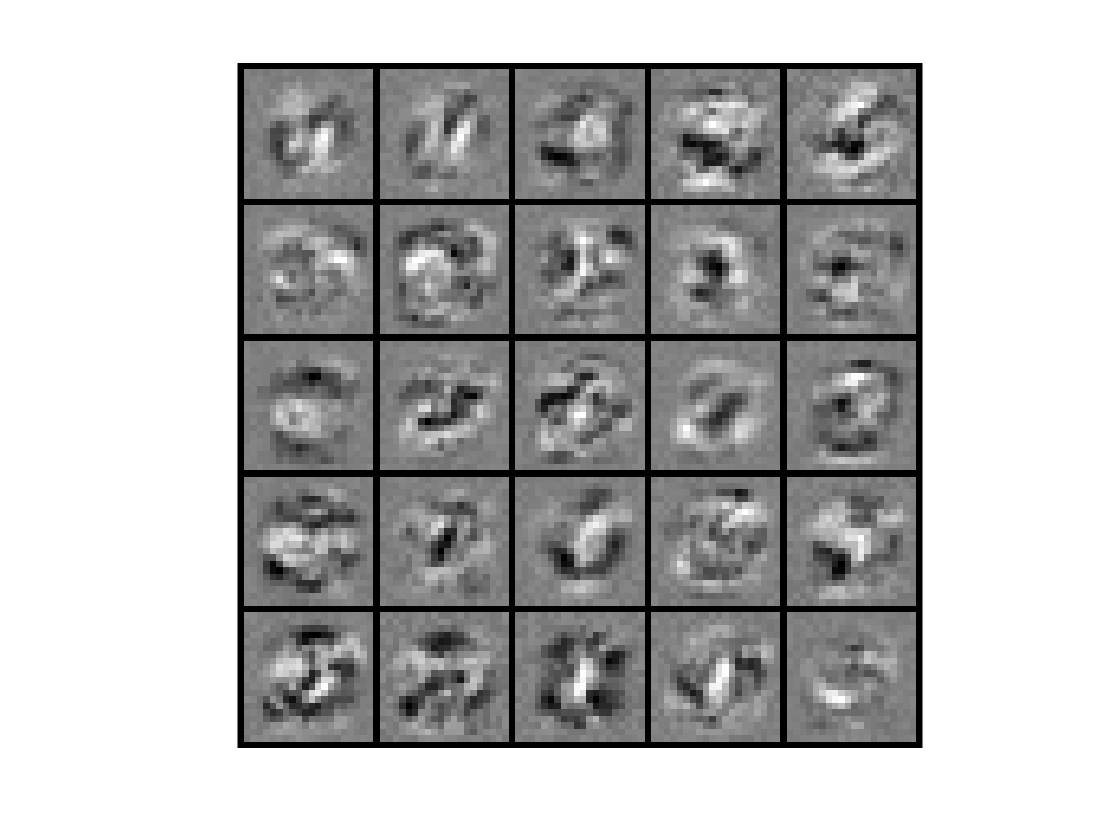


% Now, costFunction is a function that takes in only one argument (the neural network parameters)
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);


% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

% Visualize Weights 
displayData(Theta1(:, 2:end));

*You do not need to submit any solutions for this optional (ungraded) exercise.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

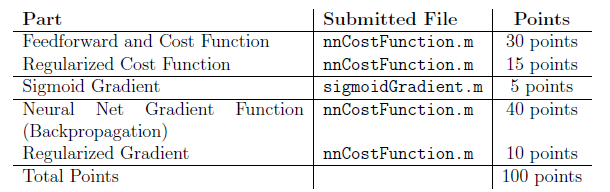

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.


.                           computeNumericalGradient.m  ex4_companion.mlx           lib                         sigmoid.m                   
..                          debugInitializeWeights.m    ex4data1.mat                nnCostFunction.m            sigmoidGradient.m           
.MATLABDriveTag             displayData.m               ex4weights.mat              predict.m                   submit.m                    
checkNNGradients.m          ex4.mlx                     fmincg.m                    randInitializeWeights.m     

